% Load YALMIP
addpath(genpath('C:\Users\Lu34\OneDrive\Desktop\Year 4 Project II\Matlab simulation\acn_data\final codes\YALMIP-master')); % Add path
yalmip('clear')
load profiles.mat

% Specify the path to the CSV file
csvFilePath = 'C:\Users\Lu34\OneDrive\Desktop\Year 4 Project II\Matlab simulation\acn_data\final codes\combined_hourly_csv.csv';

opts = detectImportOptions(csvFilePath);
opts.VariableNamingRule = 'preserve';

% Read the CSV file into a table in MATLAB
dataTable = readtable(csvFilePath, opts);

% Display the table
disp(dataTable);

           Hour            Location1_kWh         Location2_kWh              Location3_kWh         Total_kWh
    ___________________    _____________    _______________________    _______________________    _________

                    NaT           NaN       {'kWhDeliveredPerHour'}    {'kWhDeliveredPerHour'}         NaN 
    2018-04-25 11:00:00         2.644       {0×0 char             }    {0×0 char             }       2.644 
    2018-04-25 12:00:00         2.644       {0×0 char             }    {0×0 char             }       2.644 
    2018-04-25 13:00:00        1.3188       {0×0 char             }    {0×0 char             }      1.3188 
    2018-04-25 14:00:00        1.2953       {0×0 char             }    {0×0 char             }      1.2953 
    2018-04-25 15:00:00       0.76793       {0×0 char             }    {0

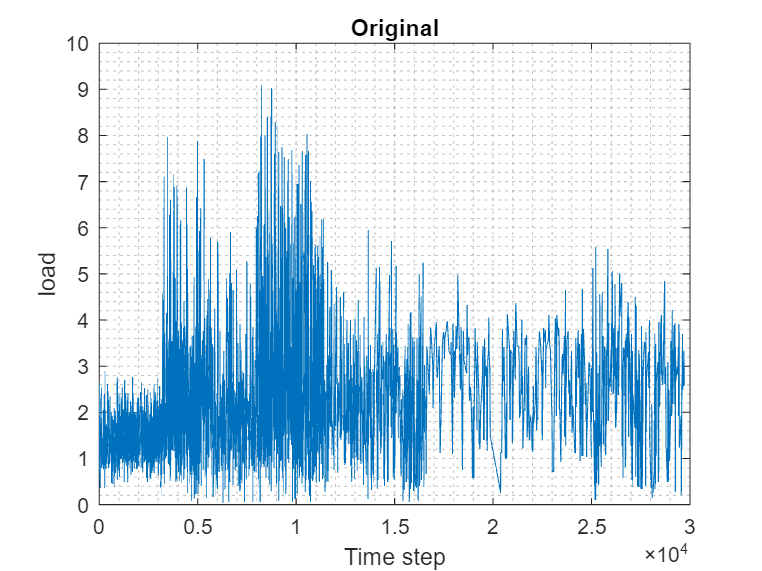


% Extract the second column
data = dataTable.Total_kWh(2:end); 

% Interpolate NaN values using linear interpolation
data = fillmissing(data, 'linear');


% data = load;

% Continue with the rest of your MATLAB script using the loaded 'data'
figure;
plot(data);
xlabel("Time step");
ylabel("load");
title("Original");
grid minor;



% Split the data into training, validation, and test sets
numObservations = numel(data);
numTimeStepsTrain = floor(0.8*numel(data)); % Adjust the split ratio as needed
numTimeStepsValidation = floor(0.1*numel(data));

idxTrain = 1:numTimeStepsTrain;
idxValidation = numTimeStepsTrain+1:numTimeStepsTrain+numTimeStepsValidation;
idxTest = numTimeStepsTrain+numTimeStepsValidation+1:numObservations;

dataTrain = data(idxTrain);
dataValidation = data(idxValidation);
dataTest = data(idxTest);

% Standardize the data
mu = mean(dataTrain);
sig = std(dataTrain);
mu_1 = mean(dataValidation);
sig_1 = std(dataValidation);
mu_2 = mean(dataTest);
sig_2 = std(dataTest);
mu_3 = mean(data);
sig_3 = std(data);

dataTrainStandardized = (dataTrain - mu) / sig;
dataValidationStandardized = (dataValidation - mu_1) / sig_1;
dataTestStandardized = (dataTest - mu_2) / sig_2;


% Define parameters
P = 32; % Number of past values to consider
F = 6; % Number of future values to predict

% Prepare input-output pairs for training, validation, and test sets
XTrain = [];
YTrain = [];
XValidation = [];
YValidation = [];
XTest = [];
YTest = [];

% Generate training sets
for k = P+1:length(dataTrainStandardized)-F
    XTrain(k-P,:) = dataTrainStandardized(k-P:k-1);
    YTrain(k-P,:) = dataTrainStandardized(k:k+F-1);
end

% Generate validation sets
for k = P+1:length(dataValidationStandardized)-F
    XValidation(k-P,:) = dataValidationStandardized(k-P:k-1);
    YValidation(k-P,:) = dataValidationStandardized(k:k+F-1);
end

% Generate test sets
for k = P+1:length(dataTestStandardized)-F
    XTest(k-P,:) = dataTestStandardized(k-P:k-1);
    YTest(k-P,:) = dataTestStandardized(k:k+F-1);
end

% Reshape
XTrain = XTrain';
YTrain = YTrain';
XValidation = XValidation';
YValidation = YValidation';
XTest = XTest';
YTest = YTest';

display(XTrain)

XTrain =     0.2733    0.2733   -0.8640   -0.8841   -1.3367   -1.1281   -1.1420   -1.1608   -1.0799   -1.1430   -1.1111   -1.0834   -1.0942   -1.0546   -0.9515   -0.6035   -0.4892   -0.3592   -0.5502   -1.4908   -1.5270   -1.5270   -1.5270   -1.5270   -1.2232   -1.2232   -1.1393   -1.3108   -1.4080   -1.2146   -1.1550   -1.1561   -1.1725   -1.2311   -1.2302   -1.2302   -1.2176   -1.2092   -1.0057   -0.7082   -0.6427   -0.4842   -1.2668   -1.6810   -1.6810   -1.6810   -1.6810   -1.6810   -1.6073   -1.6073
    0.2733   -0.8640   -0.8841   -1.3367   -1.1281   -1.1420   -1.1608   -1.0799   -1.1430   -1.1111   -1.0834   -1.0942   -1.0546   -0.9515   -0.6035   -0.4892   -0.3592   -0.5502   -1.4908   -1.5270   -1.5270   -1.5270   -1.5270   -1.2232   -1.2232   -1.1393   -1.3108   -1.4080   -1.2146   -1.1550   -1.1561   -1.1725   -1.2311   -1.2302   -1.2302   -1.2176   -1.2092   -1.0057   -0.7082   -0.6427   -0.4842   -1.2668   -1.6810   -1.6810   -1.6810   -1.6810   -1.6810   -1.6073   -1.6073

display(YTrain)

YTrain =    -1.1725   -1.2311   -1.2302   -1.2302   -1.2176   -1.2092   -1.0057   -0.7082   -0.6427   -0.4842   -1.2668   -1.6810   -1.6810   -1.6810   -1.6810   -1.6810   -1.6073   -1.6073   -1.5175   -1.0770   -1.0341   -0.8851   -0.8730   -0.9486   -0.9073   -0.9279   -0.8716   -0.8100   -0.8434   -0.7941   -0.5648   -0.7275   -0.6382   -0.5885   -0.5070   -0.6692   -0.7908   -0.7908   -0.7908   -0.8949   -0.8949   -0.8375   -0.7574   -0.5852   -0.5467   -0.5910   -0.1285   -0.1224   -0.1165   -0.0203
   -1.2311   -1.2302   -1.2302   -1.2176   -1.2092   -1.0057   -0.7082   -0.6427   -0.4842   -1.2668   -1.6810   -1.6810   -1.6810   -1.6810   -1.6810   -1.6073   -1.6073   -1.5175   -1.0770   -1.0341   -0.8851   -0.8730   -0.9486   -0.9073   -0.9279   -0.8716   -0.8100   -0.8434   -0.7941   -0.5648   -0.7275   -0.6382   -0.5885   -0.5070   -0.6692   -0.7908   -0.7908   -0.7908   -0.8949   -0.8949   -0.8375   -0.7574   -0.5852   -0.5467   -0.5910   -0.1285   -0.1224   -0.1165   -0.0203

display(XValidation)

XValidation =     1.0005    1.0034    1.0062    1.0091    1.0119    1.0148    1.0176    1.0205    1.0233    1.0262    1.0290    1.0319    1.0347    1.0376    1.0404    1.0433    1.0461    1.0489    1.0518    1.0546    1.0575    1.0603    1.0632    1.0660    1.0689    1.0717    1.0746    1.0774    1.0803    1.0831    1.0860    1.0888    1.0917    1.0945    1.0973    1.1002    1.1030    1.1059    1.1087    1.1116    1.1144    1.1173    1.1201    1.1230    1.1258    1.1287    1.1315    1.1344    1.1372    1.1401
    1.0034    1.0062    1.0091    1.0119    1.0148    1.0176    1.0205    1.0233    1.0262    1.0290    1.0319    1.0347    1.0376    1.0404    1.0433    1.0461    1.0489    1.0518    1.0546    1.0575    1.0603    1.0632    1.0660    1.0689    1.0717    1.0746    1.0774    1.0803    1.0831    1.0860    1.0888    1.0917    1.0945    1.0973    1.1002    1.1030    1.1059    1.1087    1.1116    1.1144    1.1173    1.1201    1.1230    1.1258    1.1287    1.1315    1.1344    1.1372    1

display(YValidation)

YValidation =     1.0917    1.0945    1.0973    1.1002    1.1030    1.1059    1.1087    1.1116    1.1144    1.1173    1.1201    1.1230    1.1258    1.1287    1.1315    1.1344    1.1372    1.1401    1.1401    1.1401    1.1401    1.1401    1.1401    0.3564    0.3564    0.3564    0.3564    0.3564    0.3317    0.3070    0.2822    0.2575    0.2328    0.2080    0.1833    0.1586    0.1339    0.1091    0.0844    0.0597    0.0349    0.0102   -0.0145   -0.0393   -0.0640   -0.0887   -0.1134   -0.1382   -0.1629   -0.1629
    1.0945    1.0973    1.1002    1.1030    1.1059    1.1087    1.1116    1.1144    1.1173    1.1201    1.1230    1.1258    1.1287    1.1315    1.1344    1.1372    1.1401    1.1401    1.1401    1.1401    1.1401    1.1401    0.3564    0.3564    0.3564    0.3564    0.3564    0.3317    0.3070    0.2822    0.2575    0.2328    0.2080    0.1833    0.1586    0.1339    0.1091    0.0844    0.0597    0.0349    0.0102   -0.0145   -0.0393   -0.0640   -0.0887   -0.1134   -0.1382   -0.1629   -0

display(XTest)

XTest =    -0.9884   -0.9145   -0.8406   -0.7667   -0.6928   -0.6189   -0.5450   -0.4711   -0.3972   -0.3233   -0.2494   -0.1755   -0.1016   -0.0277    0.0462    0.1201    0.1940    0.2679    0.3419    0.4158    0.4897    0.5636    0.6375    0.7114    0.7853    0.8592    0.9331    1.0070    1.0809    1.1548    1.2287    1.3026    1.3026    1.3026    1.1191    1.1191    1.1191    1.1191    1.1191    1.1191    1.1191    1.1114    1.1036    1.0959    1.0881    1.0803    1.0726    1.0648    1.0570    1.0493
   -0.9145   -0.8406   -0.7667   -0.6928   -0.6189   -0.5450   -0.4711   -0.3972   -0.3233   -0.2494   -0.1755   -0.1016   -0.0277    0.0462    0.1201    0.1940    0.2679    0.3419    0.4158    0.4897    0.5636    0.6375    0.7114    0.7853    0.8592    0.9331    1.0070    1.0809    1.1548    1.2287    1.3026    1.3026    1.3026    1.1191    1.1191    1.1191    1.1191    1.1191    1.1191    1.1191    1.1114    1.1036    1.0959    1.0881    1.0803    1.0726    1.0648    1.0570    1.0493 

display(YTest)

YTest =     1.3026    1.3026    1.1191    1.1191    1.1191    1.1191    1.1191    1.1191    1.1191    1.1114    1.1036    1.0959    1.0881    1.0803    1.0726    1.0648    1.0570    1.0493    1.0415    1.0338    1.0260    1.0182    1.0105    1.0027    0.9950    0.9872    0.9794    0.9717    0.9639    0.9561    0.9484    0.9406    0.9329    0.9251    0.9173    0.9096    0.9018    0.8940    0.8863    0.8785    0.8708    0.8630    0.8552    0.8475    0.8397    0.8320    0.8242    0.8164    0.8164    0.8164
    1.3026    1.1191    1.1191    1.1191    1.1191    1.1191    1.1191    1.1191    1.1114    1.1036    1.0959    1.0881    1.0803    1.0726    1.0648    1.0570    1.0493    1.0415    1.0338    1.0260    1.0182    1.0105    1.0027    0.9950    0.9872    0.9794    0.9717    0.9639    0.9561    0.9484    0.9406    0.9329    0.9251    0.9173    0.9096    0.9018    0.8940    0.8863    0.8785    0.8708    0.8630    0.8552    0.8475    0.8397    0.8320    0.8242    0.8164    0.8164    0.8164 

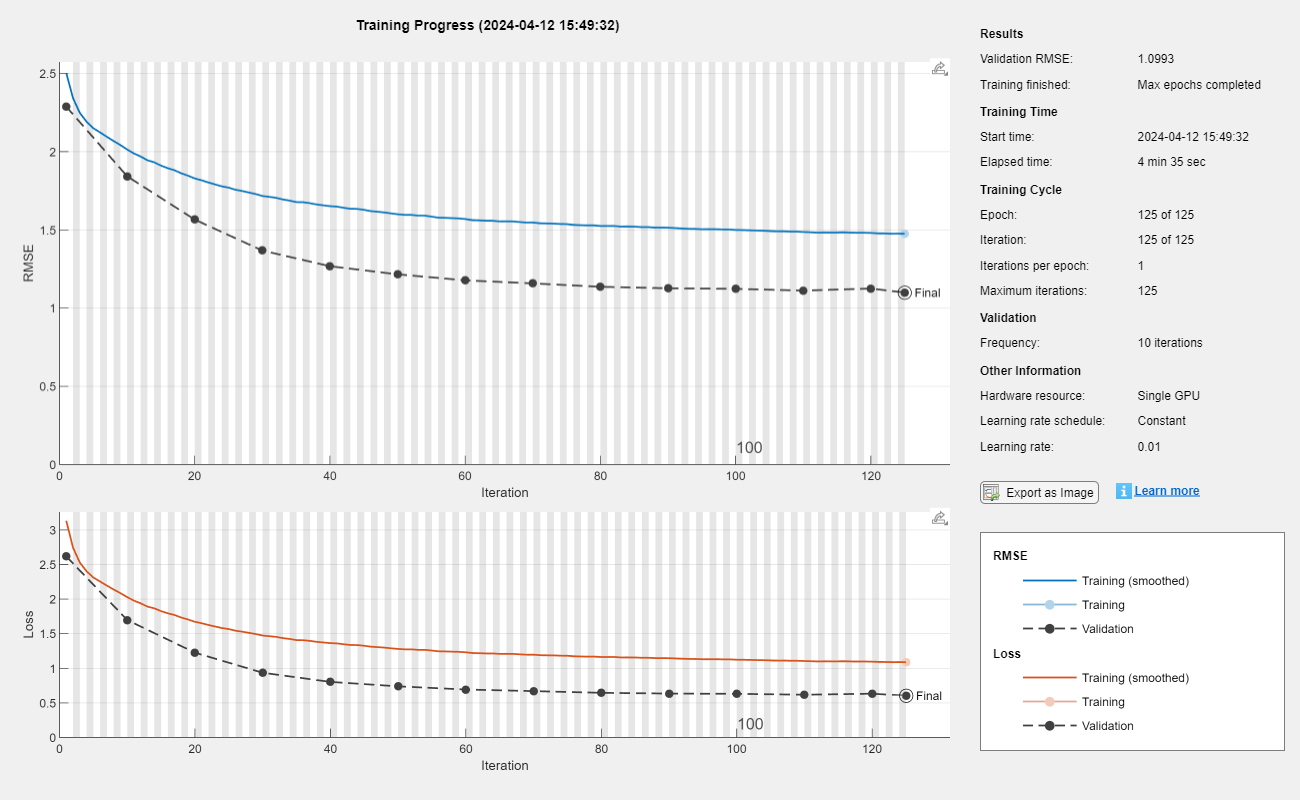

Hyperparameters: Hidden Units=12, Epochs=125, MiniBatchSize=128


Validation RMSE: 1.099342


-------------------------



% Create LSTM model

% layers = [
%     sequenceInputLayer(P, 'Name', 'input')
%     lstmLayer(numHiddenUnits, 'Name', 'lstm')
%     fullyConnectedLayer(F, 'Name', 'fc')
%     regressionLayer('Name', 'output')
% ];

% layers = [
%     sequenceInputLayer(P, 'Name', 'input')
%     lstmLayer(numHiddenUnits, 'Name', 'lstm1', 'OutputMode', 'sequence')
%     dropoutLayer(0.2, 'Name', 'dropout1')  % Optional: Dropout layer for regularization
%     lstmLayer(numHiddenUnits, 'Name', 'lstm2', 'OutputMode', 'sequence')
%     fullyConnectedLayer(64, 'Name', 'fc1')
%     reluLayer('Name', 'relu1')')
%     regressionLayer('Name', 'output')
% ];


% Define different values for hyperparameters
numHiddenUnitsList = 12;  % Add more values as needed, normally [12,24,32,48]
maxEpochsList = 125;  % Add more values as needed, normally [75,125,175]
miniBatchSizeList = 128;  % Add more values as needed, normally [32 64 128]

% Define variables to store the best hyperparameters and minimum validation RMSE
bestNumHiddenUnits = 0;
bestMaxEpochs = 0;
bestMiniBatchSize = 0;
minValidationRMSE = inf;

% Create a loop to iterate over hyperparameter values
for numHiddenUnits = numHiddenUnitsList
    for maxEpochs = maxEpochsList
        for miniBatchSize = miniBatchSizeList

            % Create or modify the layers and options based on the hyperparameters
            layers = [
                sequenceInputLayer(P, 'Name', 'input')
                lstmLayer(numHiddenUnits, 'Name', 'lstm', 'OutputMode', 'sequence')
                dropoutLayer(0.2, 'Name', 'dropout')  % Add a dropout layer
                fullyConnectedLayer(F, 'Name', 'fc')
                regressionLayer('Name', 'output')
            ];

            options = trainingOptions("adam", ...
                'MaxEpochs', maxEpochs, ...
                'MiniBatchSize', miniBatchSize, ...
                'SequencePaddingDirection', 'right', ...
                'SequenceLength', 'longest', ...
                'Shuffle', 'every-epoch', ...
                'InitialLearnRate', 0.01, ...
                'LearnRateDropFactor', 0.7, ...
                'LearnRateDropPeriod', 25, ...
                'Plots', 'training-progress', ...
                'Verbose', false, ...
                'ValidationData', {XValidation, YValidation}, ...
                'ValidationFrequency',10, ...
                'L2Regularization', 0.005);

                % 'GradientThreshold', 1, ...
                % 'InitialLearnRate', 0.01, ...
                % 'LearnRateDropFactor', 0.9, ...
                % 'LearnRateDropPeriod', 10, ...
                % 'LearnRateSchedule', 'piecewise', ..

                % 'InitialLearnRate', 0.01, ...
                % 'LearnRateDropFactor', 0.9, ...
                % 'LearnRateDropPeriod', 10, ...

            % Train the LSTM model
            [model, info] = trainNetwork(XTrain, YTrain, layers, options);

            % Extract the validation RMSE from the training progress
            validationRMSE = info.ValidationRMSE(end);

            % Compare with the minimum validation RMSE
            if validationRMSE < minValidationRMSE
                minValidationRMSE = validationRMSE;
                bestNumHiddenUnits = numHiddenUnits;
                bestMaxEpochs = maxEpochs;
                bestMiniBatchSize = miniBatchSize;
            end

            % Display or store results, such as RMSE, for each hyperparameter combination
            fprintf('Hyperparameters: Hidden Units=%d, Epochs=%d, MiniBatchSize=%d\n', numHiddenUnits, maxEpochs, miniBatchSize);
            fprintf('Validation RMSE: %f\n', validationRMSE);
            fprintf('-------------------------\n');
        end
    end
end



% Display the best hyperparameters and minimum validation RMSE
fprintf('Best Hyperparameters: Hidden Units=%d, Epochs=%d, MiniBatchSize=%d\n', bestNumHiddenUnits, bestMaxEpochs, bestMiniBatchSize);

Best Hyperparameters: Hidden Units=12, Epochs=125, MiniBatchSize=128


fprintf('Minimum Validation RMSE: %f\n', minValidationRMSE);

Minimum Validation RMSE: 1.099342


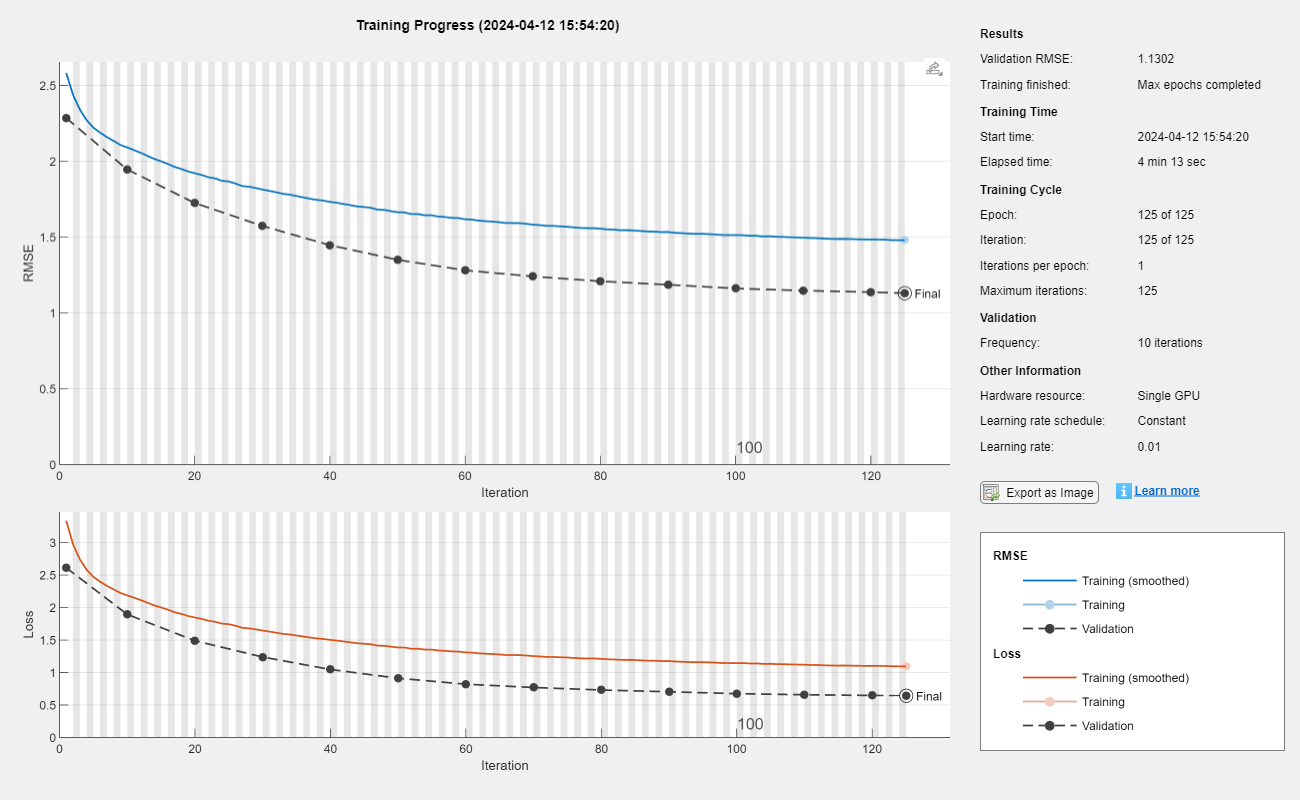


% Define the LSTM model architecture with the best hyperparameters
layers1 = [
    sequenceInputLayer(P, 'Name', 'input1')
    lstmLayer(bestNumHiddenUnits, 'Name', 'lstm1', 'OutputMode', 'sequence')
    dropoutLayer(0.2, 'Name', 'dropout1')  % Add a dropout layer
    fullyConnectedLayer(F, 'Name', 'fc1')
    regressionLayer('Name', 'output1')
    ];

options1 = trainingOptions("adam", ...
    'MaxEpochs', bestMaxEpochs, ...
    'MiniBatchSize', bestMiniBatchSize, ...
    'SequencePaddingDirection', 'right', ...
    'SequenceLength', 'longest', ...
    'Shuffle', 'every-epoch', ...
    'InitialLearnRate', 0.01, ...
    'LearnRateDropFactor', 0.7, ...
    'LearnRateDropPeriod', 25, ...
    'Plots', 'training-progress', ...
    'Verbose', false, ...
    'ValidationData', {XValidation, YValidation}, ...
    'ValidationFrequency',10, ...
    'L2Regularization', 0.005);


% Train the LSTM model
finalModel = trainNetwork(XTrain, YTrain, layers1, options1);


% Reset the model's state before making predictions
finalModel = resetState(finalModel);

% Add the testing and evaluation code here
SizeofXTest = size(XTest);
numXTest = SizeofXTest(2);
YPredicted_Test = zeros(F,numXTest); % Initialize the matrix to store predicted values zeros(F,numXTest)

for i = 1:numXTest
    % Extract the current input sequence
    currentSequence = XTest(:, i);

    % Reshape the input sequence to match the feature dimension of the model
    currentSequence = reshape(currentSequence, [P, 1, 1]);  % Reshape for LSTM input

    % Make a prediction for the next F time steps
    % Update YPredicted with the current prediction values
    currentPrediction = predict(finalModel, currentSequence, 'ExecutionEnvironment', 'cpu');  % Predict on GPU/CPU;

    % Update YPredicted with the current prediction values
    % Loop to fill each column of YPredicted
    for j = 1:F
        YPredicted_Test(j, i) = currentPrediction(j);
    end
end
% Display mean and standard deviation before destandardization
disp(['Before De-standardization: Mean(YTest): ' num2str(mean(YTest(:)))]);

Before De-standardization: Mean(YTest): -0.0031564


disp(['Std(YTest): ' num2str(std(YTest(:)))]);

Std(YTest): 1.0029



% De-standardize the predictions and testing output using the same mu and sig
YPredicted_Test = sig_2 .* YPredicted_Test + mu_2;
YTest = sig_2 .* YTest + mu_2;

% Display mean and standard deviation after destandardization
disp(['After De-standardization: Mean(YTest): ' num2str(mean(YTest(:)))]);

After De-standardization: Mean(YTest): 2.3303


disp(['Std(YTest): ' num2str(std(YTest(:)))]);

Std(YTest): 1.0563


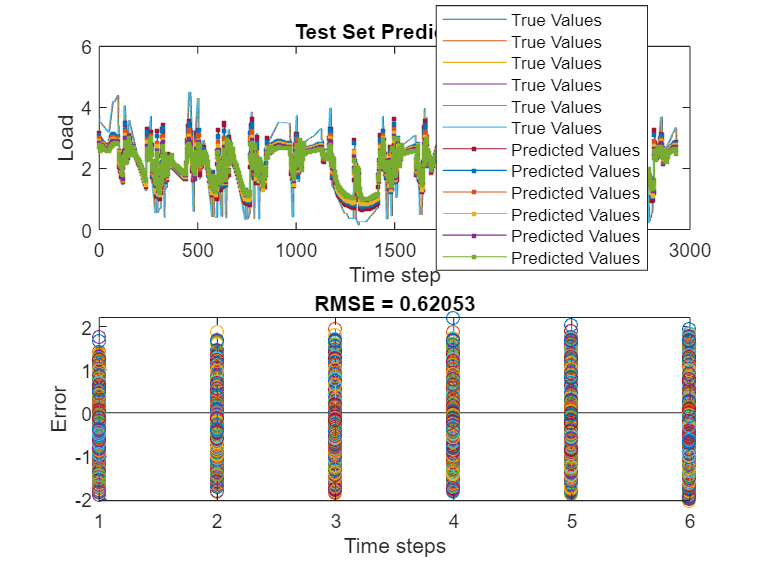


rmse = sqrt(mean((YPredicted_Test(:) - YTest(:)).^2));

% Visualize the results
figure;
subplot(2,1,1)
plot(1:length(YTest), YTest, '-','DisplayName', 'True Values');
hold on;
plot(1:length(YPredicted_Test), YPredicted_Test, '.-', 'DisplayName', 'Predicted Values');
xlabel("Time step");
ylabel("Load");
title("Test Set Predictions");
legend('Location', 'Best');
hold off;

subplot(2,1,2)
stem(YPredicted_Test - YTest)
xlabel("Time steps")
ylabel("Error")
title("RMSE = " + rmse)



YPredicted_Test_flatten = YPredicted_Test(1,:)

YPredicted_Test_flatten =     3.1827    3.1661    3.1360    2.9842    2.9477    2.9355    2.9533    2.9391    2.9198    2.9280    2.9209    2.8970    2.8848    2.8685    2.8676    2.8672    2.8648    2.8416    2.8548    2.8408    2.8456    2.8509    2.8285    2.8225    2.8033    2.7934    2.7750    2.7847    2.7648    2.7739    2.7600    2.7695    2.7537    2.7667    2.7618    2.7580    2.7548    2.7514    2.7485    2.7451    2.7423    2.7394    2.7365    2.7336    2.7307    2.7277    2.7247    2.7217    2.7186    2.7208


YTest_flatten = YTest(1,:)

YTest_flatten =     3.7056    3.7056    3.5123    3.5123    3.5123    3.5123    3.5123    3.5123    3.5123    3.5041    3.4960    3.4878    3.4796    3.4714    3.4633    3.4551    3.4469    3.4387    3.4306    3.4224    3.4142    3.4060    3.3979    3.3897    3.3815    3.3733    3.3652    3.3570    3.3488    3.3406    3.3325    3.3243    3.3161    3.3079    3.2998    3.2916    3.2834    3.2752    3.2671    3.2589    3.2507    3.2425    3.2344    3.2262    3.2180    3.2098    3.2017    3.1935    3.1935    3.1935


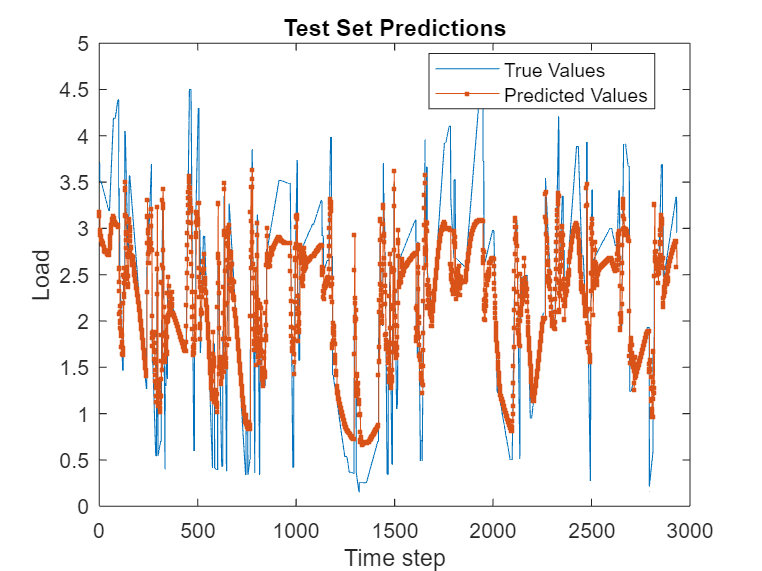


figure;
plot(1:length(YTest_flatten), YTest_flatten, '-','DisplayName', 'True Values');
hold on;
plot(1:length(YPredicted_Test_flatten), YPredicted_Test_flatten, '.-', 'DisplayName', 'Predicted Values');
xlabel("Time step");
ylabel("Load");
title("Test Set Predictions");
legend('Location', 'Best');
hold off;



% Set YPredicted_Test_flatten as predicted_load
predicted_load = YPredicted_Test_flatten';

% MPC Parameters
t_end = 720;    % Simulation time (h), one week
x=1: 1: t_end;
x_1=1: 1: t_end+1;
sigma = 0.0042;    % Self-discharge rate of the battery
eta_cd = 0.95/1.05;   % Energy conversion efficiency of the battery for charging/discharging
P_s_M = 100;     % Maximum power exchanged with the storage system (kW)
s_M = 400;        % Maximum state value (kWh)
s_m = 40;       % Minimum state value
T_s = 1; % Sampling time (h)
T = 6; % Prediction horizon for MPC (h)

P_l_t = predicted_load; % Define your load power profile after prediction

L = length(predicted_load);

P_r_t = pv(1:L); % Define your renewable energy profile 
p_t = price(1:L);   % Define your electricity price profile (euros/MWh)

% Reshape P_l_t, P_r_t, and P_t, to ensure they has the same dimensions as the other vectors
P_l_t_reshaped = P_l_t';
P_r_t_reshaped = P_r_t';
p_t_reshaped = p_t';

% Initialize variables
P_s_t = zeros(1, t_end); % Power exchange with microgrid
P_g_t = zeros(1, t_end); % Power exchange with utility grid
s_t = zeros(1, t_end+1); % State variable

cumulative_cost = zeros(1, t_end);

% Define decision variables for the prediction horizon
P_s_future = sdpvar(1, T);
s_future = sdpvar(1, T+1);


% MPC Loop
for t = 1:t_end

    s_t(1) = 200; % Initial state of s_t
    if t == 1
        s_future(1) = s_t(1);
    else
        s_future(1) = s_t(t);
    end

    %disp(['s_t before update: ' num2str(s_t(t))]);

    % MPC Optimization Problem
    % Objective function
    obj = -sum(p_t_reshaped(t:t+T-1) .* (P_r_t_reshaped(t:t+T-1) - P_l_t_reshaped(t:t+T-1) - P_s_future));

    constr1 = [P_s_future <= P_s_M, P_s_future >= -P_s_M, s_future <= s_M, s_future >= s_m]; 
    % Define the state evolution constraint
    state_evolution_constraint = s_future(2:T+1) == (1 - sigma) * s_future(1:T) + eta_cd * T_s * P_s_future(1:T);

    % Append state evolution constraint
    constr2 = [constr1, state_evolution_constraint];


    % Optimize the problem using fmincon solver
    options = sdpsettings('solver', 'fmincon', 'fmincon.TolFun', 1e-6, 'fmincon.TolCon', 1e-6); 

    % Add this inside the MPC loop, before the optimize() call
    disp(['Iteration: ' num2str(t) ', Objective: ' num2str(value(obj))]);
    disp(['P_s_future: ' num2str(value(P_s_future))]);
    disp(['s_future: ' num2str(value(s_future))]);

    optimize(constr2, obj, options);

    % Retrieve optimized values
    P_s_t(t) = value(P_s_future(1));
    P_g_t(t) = value(P_r_t_reshaped(t) - P_l_t_reshaped(t) - P_s_t(t));

    % Microgrid (uG)
    % disp(['s_t_optimized: ' num2str(s_t(t))]);

    % Update state based on the given dynamics
    s_t(t+1) = (1 - sigma) * s_t(t) + eta_cd * T_s * P_s_t(t);

    cumulative_cost(t) = -sum(P_g_t(1:t) .* p_t_reshaped(1:t)./1000);

    %disp(['s_t_update: ' num2str(s_t(t+1))]);

    % % Display progress
    disp(['Time step: ' num2str(t) ', P_s_t: ' num2str(P_s_t(t)) ', P_g_t: ' num2str(P_g_t(t)) ', s_t: ' num2str(s_t(t+1))]);

end

Iteration: 1, Objective: NaN


P_s_future: NaN  NaN  NaN  NaN  NaN  NaN


s_future: 200  NaN  NaN  NaN  NaN  NaN  NaN


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    7.225388e+02    1.582e+02    1.273e+01
    1       2   -2.793086e+03    9.240e+01    1.248e+01    6.032e+01
    2       3   -5.403595e+03    4.316e+01    1.154e+01    4.518e+01
    3       4   -5.419224e+03    4.286e+01    6.327e+00    2.616e-01
    4       5   -7.229821e+03    4.094e+00    6.327e+00    5.317e+01
    5       6   -7.426842e+03    1.902e-01    2.279e+00    7.471e+00
    6       7   -7.428284e+03    1.800e-01    2.279e+00    3.135e-01
    7       8   -7.490157e+03    5.897e-02    2.279e+00    1.874e+01
    8       9   -7.490445e+03    5.882e-02    7.518e-01    9.340e-02
    9      10   -7.493259e+03    2.132e-03    1.267e-02    8.272e-02
   10      11   -7.493386e+03    1.025e-05    2.651e-03    6.023e-03
   11      12

Time step: 1, P_s_t: -100, P_g_t: 96.8173, s_t: 108.6838


Iteration: 2, Objective: -6566.241


P_s_future: -100     -75.4092     0.185696     0.185681     0.185684      0.18567


s_future: 108.6838      108.6838      40.00001      40.00002      40.00001      40.00001            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    6.709304e+02    6.724e+01    1.351e+01
    1       2   -6.136356e+02    4.026e+01    1.290e+01    2.440e+01
    2       3   -1.929862e+03    1.198e+01    6.356e+00    2.611e+01
    3       4   -2.251450e+03    5.365e+00    2.606e+00    7.590e+00
    4       5   -2.429951e+03    2.259e+00    2.606e+00    9.118e+00
    5       6   -2.433133e+03    2.212e+00    2.606e+00    2.760e-01
    6       7   -2.562495e+03    1.282e+00    2.606e+00    2.327e+01
    7       8   -2.562998e+03    1.280e+00    2.606e+00    1.155e-01
    8       9   -2.570679e+03    1.142e+00    1.350e+00    4.607e-01
    9      10   -2.654747e+03    7.105e-15    1.342e+00    1.339e+01
   10      11   -2.799196e+03    7.105e-15    1.342e+00    6.474e+01
   11      12

Time step: 2, P_s_t: -75.4092, P_g_t: 72.2431, s_t: 40


Iteration: 3, Objective: -2378.7244


P_s_future: -75.4092     0.185684     0.185684     0.982955          100         -100


s_future: 40            40            40            40      40.72134      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    6.435396e+02    1.158e+00    1.415e+01
    1       2    6.316682e+02    6.962e-01    7.120e+00    1.794e+00
    2       3    6.546260e+02    2.341e-01    2.791e+00    2.703e+00
    3       4    6.412316e+02    7.105e-15    2.083e+00    1.076e+01
    4       5    6.087604e+02    7.105e-15    1.928e+00    1.149e+01
    5       6    2.379144e+02    1.421e-14    1.910e+00    1.319e+02
    6       7    2.360585e+02    1.421e-14    1.120e+00    6.602e-01
    7       8    2.351828e+02    2.842e-14    8.794e-01    8.902e-01
    8       9    2.290012e+02    1.421e-14    8.794e-01    5.500e+00
    9      10    2.065186e+02    2.842e-14    7.949e-01    2.055e+01
   10      11    1.532668e+02    2.842e-14    7.924e-01    4.848e+01
   11      12

Time step: 3, P_s_t: 0.18569, P_g_t: -3.3217, s_t: 40


Iteration: 4, Objective: -5920.4539


P_s_future: 0.185688     0.185687          100          100     -97.5788         -100


s_future: 40            40      40.00001      130.3082      220.2371      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -5.326585e+03    1.158e+00    1.435e+01
    1       2   -5.339306e+03    6.941e-01    6.631e+00    1.820e+00
    2       3   -5.319769e+03    2.765e-01    1.963e+00    2.806e+00
    3       4   -5.340317e+03    7.105e-15    1.689e+00    1.375e+01
    4       5   -5.365262e+03    7.105e-15    1.689e+00    8.608e+00
    5       6   -5.751002e+03    2.842e-14    1.689e+00    1.334e+02
    6       7   -5.752932e+03    2.842e-14    1.246e+00    6.676e-01
    7       8   -5.753844e+03    1.421e-14    7.770e-01    9.327e-01
    8       9   -5.760523e+03    2.842e-14    7.770e-01    5.760e+00
    9      10   -5.783744e+03    2.842e-14    7.770e-01    2.067e+01
   10      11   -5.872232e+03    4.263e-14    7.770e-01    7.842e+01
   11      12

Time step: 4, P_s_t: 0.18569, P_g_t: -3.1698, s_t: 40


Iteration: 5, Objective: -16635.7922


P_s_future: 0.185686          100          100      3.45376         -100         -100


s_future: 40.00001      40.00001      130.3082      220.2371      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.623285e+04    1.158e+00    1.398e+01
    1       2   -1.624419e+04    6.887e-01    5.371e+00    1.780e+00
    2       3   -1.621148e+04    7.105e-15    1.948e+00    4.614e+00
    3       4   -1.623052e+04    7.105e-15    1.680e+00    6.446e+00
    4       5   -1.624449e+04    7.105e-15    1.680e+00    4.796e+00
    5       6   -1.638097e+04    0.000e+00    1.680e+00    4.698e+01
    6       7   -1.652034e+04    1.421e-14    1.680e+00    4.821e+01
    7       8   -1.666134e+04    1.421e-14    1.680e+00    4.877e+01
    8       9   -1.666205e+04    2.842e-14    9.243e-01    2.457e-01
    9      10   -1.666438e+04    1.421e-14    9.207e-01    2.572e+00
   10      11   -1.668154e+04    7.105e-15    8.037e-01    1.756e+01
   11      12

Time step: 5, P_s_t: 100, P_g_t: -102.9477, s_t: 130.3082


Iteration: 6, Objective: -47923.1876


P_s_future: 100          100      3.45377         -100         -100     0.185673


s_future: 130.3082      130.3082      220.2371      222.4369      131.0265      40.00001            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -4.752083e+04    8.877e+01    1.432e+01
    1       2   -4.888386e+04    5.308e+01    1.405e+01    3.013e+01
    2       3   -5.015828e+04    1.885e+01    7.145e+00    2.895e+01
    3       4   -5.086845e+04    5.684e-14    2.397e+00    1.639e+01
    4       5   -5.088395e+04    1.421e-14    2.209e+00    5.018e+00
    5       6   -5.090872e+04    7.105e-15    2.206e+00    8.035e+00
    6       7   -5.091707e+04    7.105e-15    2.206e+00    2.755e+00
    7       8   -5.165244e+04    2.842e-14    2.206e+00    2.427e+02
    8       9   -5.165612e+04    4.263e-14    2.206e+00    1.214e+00
    9      10   -5.165789e+04    2.842e-14    7.389e-01    1.466e+00
   10      11   -5.166717e+04    5.684e-14    7.385e-01    7.387e+00
   11      12

Time step: 6, P_s_t: 100, P_g_t: -102.9355, s_t: 220.2371


Iteration: 7, Objective: -84763.1588


P_s_future: 100      4.25778         -100         -100          100         -100


s_future: 220.2371      220.2371      223.1644      131.7509      40.72134      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -8.125700e+04    1.783e+02    1.420e+01
    1       2   -8.420797e+04    1.058e+02    1.409e+01    6.133e+01
    2       3   -8.695092e+04    3.742e+01    7.489e+00    5.774e+01
    3       4   -8.738916e+04    2.652e+01    1.671e+00    9.231e+00
    4       5   -8.740271e+04    2.618e+01    1.671e+00    3.956e-01
    5       6   -8.847754e+04    7.105e-15    1.671e+00    3.453e+01
    6       7   -8.847946e+04    1.421e-14    8.196e-01    1.380e+00
    7       8   -8.848481e+04    1.421e-14    8.196e-01    3.728e+00
    8       9   -8.851707e+04    2.842e-14    8.196e-01    2.490e+01
    9      10   -8.854407e+04    2.842e-14    8.196e-01    2.070e+01
   10      11   -8.854434e+04    4.263e-14    8.196e-01    2.302e-01
   11      12

Time step: 7, P_s_t: 100, P_g_t: -102.9533, s_t: 309.7883


Iteration: 8, Objective: -125817.992


P_s_future: 100         -100         -100          100         -100     -93.5628


s_future: 309.7883      309.7883       218.011      126.6191      216.5635      125.1778            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.187936e+05    2.675e+02    1.436e+01
    1       2   -1.233058e+05    1.588e+02    1.429e+01    9.227e+01
    2       3   -1.247797e+05    1.229e+02    9.811e+00    3.037e+01
    3       4   -1.247932e+05    1.226e+02    9.811e+00    3.106e-01
    4       5   -1.283983e+05    3.399e+01    9.811e+00    1.159e+02
    5       6   -1.284184e+05    3.349e+01    2.671e+00    6.475e-01
    6       7   -1.297556e+05    1.421e-14    2.671e+00    5.508e+01
    7       8   -1.297566e+05    1.137e-13    5.963e-01    1.003e+00
    8       9   -1.297616e+05    1.421e-14    5.963e-01    4.966e+00
    9      10   -1.297862e+05    1.421e-14    5.963e-01    2.494e+01
   10      11   -1.298690e+05    2.842e-14    5.963e-01    8.397e+01
   11      12

Time step: 8, P_s_t: -100, P_g_t: 97.0609, s_t: 218.011


Iteration: 9, Objective: -157267.1028


P_s_future: -100         -100          100         -100      7.04547         -100


s_future: 218.011       218.011      126.6191      216.5635      125.1778      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.468056e+05    1.761e+02    1.362e+01
    1       2   -1.498115e+05    1.034e+02    1.349e+01    6.189e+01
    2       3   -1.525770e+05    3.563e+01    7.563e+00    5.754e+01
    3       4   -1.525936e+05    3.522e+01    4.610e+00    3.465e-01
    4       5   -1.537652e+05    6.008e+00    4.610e+00    3.837e+01
    5       6   -1.540066e+05    1.990e-13    6.798e-01    8.022e+00
    6       7   -1.540079e+05    2.842e-14    5.857e-01    1.170e+00
    7       8   -1.540132e+05    2.842e-14    5.857e-01    5.307e+00
    8       9   -1.540422e+05    2.842e-14    5.857e-01    2.939e+01
    9      10   -1.541203e+05    2.842e-14    5.857e-01    7.925e+01
   10      11   -1.541207e+05    2.842e-14    5.857e-01    3.963e-01
   11      12

Time step: 9, P_s_t: -100, P_g_t: 255.8066, s_t: 126.6191


Iteration: 10, Objective: -164774.6147


P_s_future: -100          100         -100      7.04547         -100     0.185684


s_future: 126.6191      126.6191      216.5635      125.1778      131.0265            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.580738e+05    8.510e+01    1.376e+01
    1       2   -1.594860e+05    5.065e+01    1.348e+01    2.913e+01
    2       3   -1.608473e+05    1.656e+01    6.673e+00    2.884e+01
    3       4   -1.615114e+05    2.842e-14    1.021e+00    1.417e+01
    4       5   -1.615129e+05    2.842e-14    5.901e-01    8.624e-01
    5       6   -1.615164e+05    2.842e-14    5.639e-01    2.870e+00
    6       7   -1.615481e+05    1.421e-14    5.639e-01    2.596e+01
    7       8   -1.616910e+05    1.421e-14    5.639e-01    1.174e+02
    8       9   -1.616917e+05    1.421e-14    5.639e-01    5.869e-01
    9      10   -1.616918e+05    1.421e-14    5.367e-01    3.456e-02
   10      11   -1.617005e+05    1.421e-14    4.711e-01    9.701e+00
   11      12

Time step: 10, P_s_t: 100, P_g_t: 200.3185, s_t: 216.5635


Iteration: 11, Objective: -170930.6983


P_s_future: 100         -100      7.04547         -100          100     -99.2094


s_future: 216.5635      216.5635      125.1778      131.0265            40      130.3082            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.673277e+05    1.747e+02    1.521e+01
    1       2   -1.702093e+05    1.055e+02    1.507e+01    5.883e+01
    2       3   -1.727993e+05    4.245e+01    8.201e+00    5.356e+01
    3       4   -1.732134e+05    3.245e+01    4.655e+00    8.579e+00
    4       5   -1.732239e+05    3.219e+01    4.655e+00    2.988e-01
    5       6   -1.745609e+05    2.842e-14    4.655e+00    4.354e+01
    6       7   -1.745791e+05    2.842e-14    2.115e+00    4.843e+00
    7       8   -1.746702e+05    2.842e-14    2.108e+00    2.419e+01
    8       9   -1.747107e+05    1.421e-14    2.108e+00    1.081e+01
    9      10   -1.747114e+05    1.421e-14    2.108e+00    2.351e-01
   10      11   -1.750785e+05    3.553e-14    2.108e+00    1.192e+02
   11      12

Time step: 11, P_s_t: -100, P_g_t: 928.7611, s_t: 125.1778


Iteration: 12, Objective: -153325.8625


P_s_future: -100      7.04546         -100          100      1.39883         -100


s_future: 125.1778      125.1778      131.0265      40.00001      130.3082      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.454380e+05    8.366e+01    1.712e+01
    1       2   -1.468087e+05    5.105e+01    1.673e+01    2.771e+01
    2       3   -1.479999e+05    2.198e+01    9.724e+00    2.489e+01
    3       4   -1.489361e+05    1.421e-14    3.630e+00    2.052e+01
    4       5   -1.490271e+05    1.421e-14    3.386e+00    1.495e+01
    5       6   -1.494819e+05    1.421e-14    3.302e+00    7.485e+01
    6       7   -1.495826e+05    2.842e-14    3.267e+00    1.657e+01
    7       8   -1.495836e+05    2.842e-14    3.267e+00    1.564e-01
    8       9   -1.500540e+05    4.263e-14    3.267e+00    7.819e+01
    9      10   -1.500565e+05    2.842e-14    3.267e+00    4.073e-01
   10      11   -1.501006e+05    2.842e-14    3.262e+00    1.231e+01
   11      12

Time step: 12, P_s_t: 9.5078, P_g_t: 904.6753, s_t: 133.2543


Iteration: 13, Objective: -118440.2999


P_s_future: 9.50776         -100          100          100         -100         -100


s_future: 133.2543      133.2543      42.21844      132.5173      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.125892e+05    9.170e+01    2.075e+01
    1       2   -1.140967e+05    5.672e+01    2.022e+01    3.008e+01
    2       3   -1.153763e+05    2.682e+01    1.489e+01    2.620e+01
    3       4   -1.166481e+05    1.421e-14    7.926e+00    2.840e+01
    4       5   -1.170651e+05    1.421e-14    6.288e+00    3.803e+01
    5       6   -1.184422e+05    1.421e-14    6.225e+00    1.256e+02
    6       7   -1.184491e+05    1.421e-14    4.385e+00    6.306e-01
    7       8   -1.184756e+05    2.132e-14    4.385e+00    4.360e+00
    8       9   -1.187555e+05    2.842e-14    4.385e+00    4.604e+01
    9      10   -1.195837e+05    2.842e-14    4.385e+00    1.363e+02
   10      11   -1.195878e+05    5.684e-14    4.367e+00    6.833e-01
   11      12

Time step: 13, P_s_t: 2.3164, P_g_t: 994.7622, s_t: 134.7904


Iteration: 14, Objective: -83782.7172


P_s_future: 2.31635          100          100         -100         -100         -100


s_future: 134.7904      134.7904      224.7004      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -7.498386e+04    9.323e+01    2.273e+01
    1       2   -7.651069e+04    5.774e+01    2.227e+01    3.016e+01
    2       3   -7.774843e+04    2.912e+01    1.509e+01    2.531e+01
    3       4   -7.916653e+04    2.842e-14    9.480e+00    3.205e+01
    4       5   -7.973379e+04    1.421e-14    6.319e+00    4.601e+01
    5       6   -8.209172e+04    2.842e-14    6.319e+00    1.913e+02
    6       7   -8.210379e+04    2.842e-14    5.410e+00    9.778e-01
    7       8   -8.222260e+04    2.842e-14    5.410e+00    1.047e+01
    8       9   -8.296487e+04    2.842e-14    5.410e+00    6.541e+01
    9      10   -8.296875e+04    2.842e-14    4.549e+00    3.442e-01
   10      11   -8.304836e+04    2.842e-14    4.468e+00    1.325e+01
   11      12

Time step: 14, P_s_t: 100, P_g_t: 706.4049, s_t: 224.7004


Iteration: 15, Objective: -57057.7587


P_s_future: 100          100       1.4587         -100         -100         -100


s_future: 224.7004      224.7004      314.2329      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -4.691181e+04    1.828e+02    2.297e+01
    1       2   -5.010670e+04    1.120e+02    2.275e+01    5.981e+01
    2       3   -5.260731e+04    5.686e+01    1.475e+01    4.707e+01
    3       4   -5.445875e+04    1.813e+01    6.954e+00    3.519e+01
    4       5   -5.458314e+04    1.619e+01    6.954e+00    3.691e+00
    5       6   -5.589372e+04    2.842e-14    6.476e+00    5.294e+01
    6       7   -5.854771e+04    2.842e-14    6.476e+00    2.244e+02
    7       8   -5.856111e+04    2.842e-14    6.432e+00    1.131e+00
    8       9   -5.870589e+04    1.137e-13    6.432e+00    1.307e+01
    9      10   -5.871082e+04    1.137e-13    6.432e+00    5.000e-01
   10      11   -5.994485e+04    5.684e-14    6.432e+00    1.308e+02
   11      12

Time step: 15, P_s_t: 100, P_g_t: 376.1382, s_t: 314.2329


Iteration: 16, Objective: -44241.901


P_s_future: 100      96.2539     -92.9384         -100         -100         -100


s_future: 314.2329      314.2329           400      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.963244e+04    2.719e+02    2.223e+01
    1       2   -3.503619e+04    1.654e+02    2.210e+01    8.991e+01
    2       3   -3.755932e+04    1.157e+02    1.344e+01    4.207e+01
    3       4   -3.758067e+04    1.153e+02    1.344e+01    3.741e-01
    4       5   -4.436046e+04    2.842e-14    1.344e+01    1.537e+02
    5       6   -4.442923e+04    2.274e-13    8.148e+00    8.449e+00
    6       7   -4.454081e+04    2.274e-13    6.037e+00    1.388e+01
    7       8   -4.573372e+04    5.684e-14    6.032e+00    1.440e+02
    8       9   -4.573996e+04    5.684e-14    5.300e+00    7.104e-01
    9      10   -4.587180e+04    5.684e-14    5.300e+00    1.438e+01
   10      11   -4.597939e+04    5.684e-14    5.300e+00    1.168e+01
   11      12

Time step: 16, P_s_t: 96.2539, P_g_t: 390.643, s_t: 400


Iteration: 17, Objective: -27774.8407


P_s_future: 96.2539      1.85684         -100         -100         -100      -93.027


s_future: 400           400           400      307.8438      216.0747       124.691            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -9.425225e+03    3.573e+02    2.147e+01
    1       2   -1.747013e+04    2.169e+02    2.139e+01    1.186e+02
    2       3   -1.825089e+04    2.033e+02    1.344e+01    1.153e+01
    3       4   -1.828607e+04    2.027e+02    1.344e+01    6.724e-01
    4       5   -2.403584e+04    1.140e+02    1.344e+01    1.162e+02
    5       6   -2.407319e+04    1.134e+02    1.344e+01    7.628e-01
    6       7   -2.893712e+04    3.993e+01    1.344e+01    1.212e+02
    7       8   -2.896352e+04    3.953e+01    6.697e+00    6.590e-01
    8       9   -3.151307e+04    3.411e-13    6.697e+00    7.716e+01
    9      10   -3.152420e+04    1.705e-13    6.330e+00    3.091e+00
   10      11   -3.154410e+04    1.705e-13    6.279e+00    3.240e+00
   11      12

Time step: 17, P_s_t: 1.8568, P_g_t: 197.4249, s_t: 400


Iteration: 18, Objective: -22827.6526


P_s_future: 1.85684         -100         -100         -100      -93.027     0.185684


s_future: 400           400      307.8438      216.0747       124.691            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    3.526242e+00    3.573e+02    1.902e+01
    1       2   -9.502213e+03    2.118e+02    1.895e+01    1.236e+02
    2       3   -9.672851e+03    2.092e+02    1.090e+01    2.226e+00
    3       4   -9.820579e+03    2.069e+02    1.090e+01    2.913e+00
    4       5   -1.492864e+04    1.299e+02    1.090e+01    1.011e+02
    5       6   -1.496220e+04    1.294e+02    1.090e+01    6.740e-01
    6       7   -2.038565e+04    4.505e+01    1.090e+01    1.393e+02
    7       8   -2.041376e+04    4.461e+01    2.737e+00    7.219e-01
    8       9   -2.153924e+04    2.627e+01    2.737e+00    3.553e+01
    9      10   -2.196830e+04    1.932e+01    2.737e+00    1.354e+01
   10      11   -2.315695e+04    5.684e-14    1.203e+00    3.763e+01
   11      12

Time step: 18, P_s_t: -100, P_g_t: 113.6854, s_t: 307.8438


Iteration: 19, Objective: -22012.0874


P_s_future: -100         -100         -100      -93.027     0.185684     0.185684


s_future: 307.8438      307.8438      216.0747       124.691            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    9.186906e+02    2.656e+02    1.733e+01
    1       2   -6.342609e+03    1.576e+02    1.719e+01    9.426e+01
    2       3   -7.773612e+03    1.362e+02    1.147e+01    1.859e+01
    3       4   -7.794483e+03    1.359e+02    1.147e+01    3.351e-01
    4       5   -1.375067e+04    4.346e+01    1.147e+01    1.217e+02
    5       6   -1.378284e+04    4.296e+01    2.825e+00    6.575e-01
    6       7   -1.642997e+04    4.263e-14    2.825e+00    7.163e+01
    7       8   -1.643166e+04    4.263e-14    1.608e+00    2.864e-01
    8       9   -1.643393e+04    5.684e-14    1.019e+00    1.630e+00
    9      10   -1.644437e+04    7.105e-15    1.019e+00    7.730e+00
   10      11   -1.648771e+04    1.421e-14    1.019e+00    3.257e+01
   11      12

Time step: 19, P_s_t: -100, P_g_t: 97.1452, s_t: 216.0747


Iteration: 20, Objective: -15937.9885


P_s_future: -100         -100      -93.027     0.185684     0.185684     0.185684


s_future: 216.0747      216.0747       124.691            40            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    8.544513e+02    1.742e+02    1.583e+01
    1       2   -3.819313e+03    1.029e+02    1.559e+01    6.340e+01
    2       3   -7.198870e+03    5.102e+01    9.889e+00    4.602e+01
    3       4   -7.220103e+03    5.069e+01    8.707e+00    2.831e-01
    4       5   -9.933029e+03    6.893e+00    8.707e+00    5.887e+01
    5       6   -1.017206e+04    3.061e+00    1.047e+00    5.309e+00
    6       7   -1.035304e+04    1.814e-01    9.097e-01    4.526e+00
    7       8   -1.036982e+04    2.206e-02    8.990e-01    5.215e+00
    8       9   -1.041011e+04    7.105e-15    8.990e-01    2.925e+01
    9      10   -1.041381e+04    2.132e-14    8.990e-01    2.781e+00
   10      11   -1.041383e+04    7.105e-15    1.315e-02    1.390e-02
   11      12

Time step: 20, P_s_t: -100, P_g_t: 97.1592, s_t: 124.691


Iteration: 21, Objective: -10000.3222


P_s_future: -100      -93.027     0.185684     0.185684     0.185684     0.185684


s_future: 124.691       124.691            40            40            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    7.853791e+02    8.318e+01    1.451e+01
    1       2   -1.368509e+03    4.892e+01    1.400e+01    3.091e+01
    2       3   -3.511200e+03    1.451e+01    7.267e+00    3.163e+01
    3       4   -3.989189e+03    7.034e+00    2.774e+00    7.909e+00
    4       5   -4.167055e+03    4.184e+00    1.090e+00    2.822e+00
    5       6   -4.363972e+03    1.068e+00    9.557e-01    4.224e+00
    6       7   -4.427590e+03    2.353e-01    9.557e-01    9.213e+00
    7       8   -4.467865e+03    1.298e-01    9.557e-01    2.537e+01
    8       9   -4.468040e+03    1.297e-01    6.873e-01    1.266e-01
    9      10   -4.472881e+03    5.240e-02    5.494e-03    8.582e-02
   10      11   -4.476162e+03    1.421e-14    3.661e-04    5.786e-02
   11      12

Time step: 21, P_s_t: -93.027, P_g_t: 90.1813, s_t: 40


Iteration: 22, Objective: -4356.2646


P_s_future: -93.027     0.185684     0.185684     0.185684     0.185684     0.185684


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    7.227725e+02    1.158e+00    1.401e+01
    1       2    7.149798e+02    6.867e-01    2.580e+00    1.789e+00
    2       3    7.473036e+02    2.777e-01    5.488e-01    7.661e-01
    3       4    7.677658e+02    3.594e-02    1.689e-01    5.609e-01
    4       5    7.707498e+02    7.105e-15    1.580e-01    3.113e-01
    5       6    7.704729e+02    7.105e-15    1.291e-01    6.514e-01
    6       7    7.704541e+02    7.105e-15    1.818e-03    3.175e-03
    7       8    7.704321e+02    7.105e-15    3.799e-04    2.541e-03
    8       9    7.704320e+02    7.105e-15    2.000e-06    1.195e-05

Local minimum found that satisfies the constraints.

Optimization complete

Time step: 22, P_s_t: 0.18568, P_g_t: -3.0366, s_t: 40


Iteration: 23, Objective: 708.0394


P_s_future: 0.18568     0.18568     0.18568     0.18568     0.18569     0.18568


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    6.640527e+02    1.158e+00    1.368e+01
    1       2    6.581840e+02    6.875e-01    2.582e+00    1.618e+00
    2       3    6.900328e+02    2.385e-01    5.158e-01    8.764e-01
    3       4    7.082091e+02    9.280e-03    2.759e-01    5.565e-01
    4       5    7.081041e+02    4.660e-04    2.750e-01    7.873e-01
    5       6    7.080667e+02    2.995e-04    9.220e-02    6.729e-02
    6       7    7.080399e+02    1.024e-04    2.188e-02    8.525e-02
    7       8    7.080406e+02    0.000e+00    6.981e-04    2.037e-03
    8       9    7.080394e+02    7.105e-15    4.748e-05    5.814e-04
    9      10    7.080394e+02    7.105e-15    4.000e-07    2.139e-06

Local min

Time step: 23, P_s_t: 0.18568, P_g_t: -3.0141, s_t: 40


Iteration: 24, Objective: 670.8092


P_s_future: 0.18568     0.18568     0.18568     0.18568     0.18568     0.18568


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    6.289782e+02    1.158e+00    1.356e+01
    1       2    6.226091e+02    6.890e-01    2.597e+00    1.574e+00
    2       3    6.515562e+02    2.677e-01    5.390e-01    7.834e-01
    3       4    6.717033e+02    7.105e-15    3.146e-01    6.199e-01
    4       5    6.710728e+02    7.105e-15    2.895e-01    5.714e-01
    5       6    6.709941e+02    7.105e-15    1.207e-01    1.042e-01
    6       7    6.709129e+02    7.105e-15    8.450e-02    2.025e-01
    7       8    6.708364e+02    7.105e-15    8.450e-02    4.265e-01
    8       9    6.708103e+02    7.105e-15    7.755e-02    2.012e-01
    9      11    6.708105e+02    7.105e-15    3.877e-02    1.627e-03
   10      12    6.708102e+02    7.105e-15    2.001e-04    1.894e-03
   11      13

Time step: 24, P_s_t: 0.18568, P_g_t: -3.0082, s_t: 40


Iteration: 25, Objective: 647.047


P_s_future: 0.18568     0.18568     0.18569     0.18568     0.18569     0.18568


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    6.065752e+02    1.158e+00    1.372e+01
    1       2    5.994355e+02    6.918e-01    2.632e+00    1.503e+00
    2       3    6.279530e+02    2.686e-01    7.119e-01    7.988e-01
    3       4    6.471669e+02    7.105e-15    3.577e-01    7.567e-01
    4       5    6.464261e+02    7.105e-15    2.514e-01    7.801e-01
    5       6    6.462652e+02    7.105e-15    2.456e-01    2.876e-01
    6       7    6.458086e+02    7.105e-15    2.456e-01    1.130e+00
    7       8    6.433767e+02    7.105e-15    2.456e-01    6.872e+00
    8       9    6.247680e+02    7.105e-15    2.456e-01    5.317e+01
    9      10    5.901082e+02    7.105e-15    2.456e-01    9.914e+01
   10      11    5.899349e+02    2.132e-14    2.456e-01    4.957e-01
   11      13

Time step: 25, P_s_t: 0.18568, P_g_t: -2.989, s_t: 40


Iteration: 26, Objective: 374.1472


P_s_future: 0.185684     0.185685     0.185684     0.982956          100         -100


s_future: 40            40            40            40      40.72134      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    6.026538e+02    1.158e+00    1.454e+01
    1       2    5.921827e+02    6.988e-01    3.036e+00    1.509e+00
    2       3    6.358151e+02    7.105e-15    1.658e+00    2.529e+00
    3       4    6.275566e+02    7.105e-15    1.495e+00    4.169e+00
    4       5    6.230762e+02    7.105e-15    1.456e+00    2.357e+00
    5       6    5.718060e+02    7.105e-15    1.456e+00    2.719e+01
    6       7    3.437651e+02    7.105e-15    1.456e+00    1.209e+02
    7       8    3.426248e+02    2.842e-14    1.038e+00    6.047e-01
    8       9    3.425694e+02    2.842e-14    2.356e-01    1.238e-01
    9      10    3.419149e+02    2.132e-14    2.356e-01    1.830e+00
   10      11    3.386976e+02    3.553e-14    2.355e-01    9.152e+00
   11      12

Time step: 26, P_s_t: 0.18571, P_g_t: -2.9791, s_t: 40


Iteration: 27, Objective: -708.9219


P_s_future: 0.185705     0.185683          100          100     -97.5788         -100


s_future: 40.00002      40.00002      40.00002      130.3082      220.2371      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    5.401255e+02    1.158e+00    1.672e+01
    1       2    5.170455e+02    7.095e-01    9.608e+00    2.022e+00
    2       3    5.084394e+02    3.447e-02    4.428e+00    1.008e+01
    3       4    3.668222e+02    1.691e-02    3.851e+00    2.557e+01
    4       5   -3.628184e+02    7.816e-03    3.589e+00    1.308e+02
    5       6   -3.664786e+02    7.794e-03    1.918e+00    6.560e-01
    6       7   -3.702828e+02    2.132e-14    1.484e+00    2.275e+00
    7       8   -3.917790e+02    7.105e-15    1.484e+00    1.137e+01
    8       9   -4.986964e+02    2.842e-14    1.484e+00    5.668e+01
    9      10   -7.141470e+02    2.842e-14    1.484e+00    1.142e+02
   10      11   -7.152243e+02    2.842e-14    8.961e-01    5.711e-01
   11      12

Time step: 27, P_s_t: 0.18567, P_g_t: -2.9607, s_t: 40


Iteration: 28, Objective: -10783.4112


P_s_future: 0.185673          100          100      3.45377         -100         -100


s_future: 40.00001      40.00001      130.3082      220.2371      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -7.988680e+03    1.158e+00    1.969e+01
    1       2   -8.035016e+03    7.169e-01    1.507e+01    3.003e+00
    2       3   -8.128401e+03    2.559e-01    1.230e+01    1.380e+01
    3       4   -9.291355e+03    2.132e-14    1.077e+01    1.277e+02
    4       5   -1.009385e+04    2.842e-14    8.905e+00    8.671e+01
    5       6   -1.009832e+04    2.842e-14    5.210e+00    4.981e-01
    6       7   -1.031994e+04    2.842e-14    5.210e+00    3.960e+01
    7       8   -1.059764e+04    2.842e-14    5.210e+00    4.963e+01
    8       9   -1.059905e+04    2.842e-14    1.392e+00    2.526e-01
    9      10   -1.060432e+04    2.842e-14    1.392e+00    2.801e+00
   10      11   -1.063074e+04    2.842e-14    1.392e+00    1.401e+01
   11      12

Time step: 28, P_s_t: 100, P_g_t: -102.7847, s_t: 130.3082


Iteration: 29, Objective: -29813.8548


P_s_future: 100          100          100     -95.1082         -100         -100


s_future: 130.3082      130.3082      220.2371      309.7883      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.547529e+04    8.877e+01    2.071e+01
    1       2   -2.693349e+04    5.446e+01    2.027e+01    2.912e+01
    2       3   -2.812856e+04    2.621e+01    1.316e+01    2.476e+01
    3       4   -2.933812e+04    2.842e-14    6.665e+00    2.756e+01
    4       5   -2.967433e+04    1.421e-14    4.932e+00    3.382e+01
    5       6   -3.135371e+04    2.842e-14    4.932e+00    1.690e+02
    6       7   -3.139429e+04    2.842e-14    4.817e+00    4.083e+00
    7       8   -3.140088e+04    5.684e-14    4.817e+00    7.498e-01
    8       9   -3.263683e+04    2.842e-14    4.817e+00    1.418e+02
    9      10   -3.276492e+04    2.842e-14    4.817e+00    1.470e+01
   10      11   -3.276568e+04    2.842e-14    4.817e+00    8.936e-02
   11      12

Time step: 29, P_s_t: 100, P_g_t: -102.7648, s_t: 220.2371


Iteration: 30, Objective: -56570.5685


P_s_future: 100          100      6.35053         -100         -100         -100


s_future: 220.2371      220.2371      309.7883      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -4.791093e+04    1.783e+02    2.091e+01
    1       2   -5.094780e+04    1.089e+02    2.071e+01    5.864e+01
    2       3   -5.337587e+04    5.326e+01    1.297e+01    4.727e+01
    3       4   -5.501646e+04    1.708e+01    5.890e+00    3.214e+01
    4       5   -5.505659e+04    1.637e+01    5.397e+00    1.170e+00
    5       6   -5.618345e+04    2.558e-13    5.134e+00    4.623e+01
    6       7   -5.714714e+04    5.684e-14    5.133e+00    1.015e+02
    7       8   -5.788225e+04    5.684e-14    5.081e+00    7.650e+01
    8       9   -5.788628e+04    5.684e-14    5.081e+00    4.193e-01
    9      10   -5.851799e+04    2.558e-13    5.081e+00    7.291e+01
   10      11   -5.910430e+04    2.274e-13    5.081e+00    6.767e+01
   11      12

Time step: 30, P_s_t: 100, P_g_t: -102.7739, s_t: 309.7883


Iteration: 31, Objective: -86496.3862


P_s_future: 100          100     -91.7974         -100         -100         -100


s_future: 309.7883      309.7883      398.9634      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -7.414351e+04    2.675e+02    1.931e+01
    1       2   -7.930339e+04    1.599e+02    1.921e+01    9.083e+01
    2       3   -8.164215e+04    1.111e+02    1.129e+01    4.127e+01
    3       4   -8.166223e+04    1.107e+02    1.129e+01    3.729e-01
    4       5   -8.759825e+04    3.112e+00    1.129e+01    1.419e+02
    5       6   -8.779991e+04    1.705e-13    4.791e+00    7.332e+00
    6       7   -8.795106e+04    5.684e-14    4.718e+00    2.649e+01
    7       8   -8.855235e+04    5.684e-14    4.718e+00    7.346e+01
    8       9   -8.855557e+04    5.684e-14    4.718e+00    3.841e-01
    9      10   -8.900223e+04    2.842e-14    4.718e+00    7.041e+01
   10      11   -8.929659e+04    2.842e-14    4.718e+00    4.640e+01
   11      12

Time step: 31, P_s_t: 100, P_g_t: -102.76, s_t: 398.9634


Iteration: 32, Objective: -112652.4089


P_s_future: 100      2.99773         -100         -100         -100     -93.0269


s_future: 398.9634      398.9634           400      307.8438      216.0746      124.6909            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -9.740767e+04    3.563e+02    1.790e+01
    1       2   -1.052910e+05    2.121e+02    1.785e+01    1.219e+02
    2       3   -1.057582e+05    2.036e+02    1.203e+01    7.240e+00
    3       4   -1.058049e+05    2.028e+02    1.203e+01    9.951e-01
    4       5   -1.109657e+05    1.166e+02    1.203e+01    1.130e+02
    5       6   -1.109998e+05    1.160e+02    1.203e+01    7.588e-01
    6       7   -1.155475e+05    3.991e+01    1.203e+01    1.261e+02
    7       8   -1.155723e+05    3.950e+01    4.416e+00    6.893e-01
    8       9   -1.178872e+05    3.979e-13    4.416e+00    7.848e+01
    9      10   -1.178943e+05    2.842e-13    4.416e+00    1.351e+00
   10      11   -1.180098e+05    5.684e-14    4.416e+00    2.556e+01
   11      12

Time step: 32, P_s_t: 2.9978, P_g_t: -3.8445, s_t: 400


Iteration: 33, Objective: -146338.9477


P_s_future: 2.99778         -100         -100         -100      -93.027     0.185684


s_future: 400           400      307.8438      216.0747       124.691            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.265139e+05    3.573e+02    1.657e+01
    1       2   -1.350618e+05    2.157e+02    1.652e+01    1.209e+02
    2       3   -1.351085e+05    2.149e+02    1.082e+01    6.606e-01
    3       4   -1.355689e+05    2.072e+02    1.082e+01    1.016e+01
    4       5   -1.400732e+05    1.317e+02    1.082e+01    9.942e+01
    5       6   -1.401038e+05    1.311e+02    1.082e+01    6.886e-01
    6       7   -1.444908e+05    5.506e+01    1.082e+01    1.265e+02
    7       8   -1.445139e+05    5.466e+01    3.658e+00    6.673e-01
    8       9   -1.454861e+05    3.585e+01    3.658e+00    3.646e+01
    9      10   -1.473498e+05    1.705e-13    3.658e+00    6.998e+01
   10      11   -1.473505e+05    1.705e-13    1.664e+00    2.010e-01
   11      12

Time step: 33, P_s_t: -100, P_g_t: 254.636, s_t: 307.8438


Iteration: 34, Objective: -158035.345


P_s_future: -100         -100         -100      -93.027     0.185684     0.185684


s_future: 307.8438      307.8438      216.0747       124.691            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.380551e+05    2.656e+02    1.674e+01
    1       2   -1.444084e+05    1.604e+02    1.661e+01    9.208e+01
    2       3   -1.458501e+05    1.364e+02    1.213e+01    2.096e+01
    3       4   -1.458689e+05    1.361e+02    1.213e+01    3.310e-01
    4       5   -1.507737e+05    5.088e+01    1.213e+01    1.129e+02
    5       6   -1.507998e+05    5.043e+01    3.669e+00    6.013e-01
    6       7   -1.520012e+05    2.728e+01    3.669e+00    3.859e+01
    7       8   -1.534304e+05    5.684e-14    3.669e+00    4.624e+01
    8       9   -1.534347e+05    1.421e-14    2.022e+00    1.134e+00
    9      10   -1.534445e+05    1.421e-14    2.022e+00    3.967e+00
   10      11   -1.534934e+05    1.421e-14    2.022e+00    1.985e+01
   11      12

Time step: 34, P_s_t: -100, P_g_t: 416.1552, s_t: 216.0747


Iteration: 35, Objective: -149350.7676


P_s_future: -100         -100      -93.027     0.185684          100     -99.2094


s_future: 216.0747      216.0747       124.691            40            40      130.3082            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.343781e+05    1.742e+02    1.820e+01
    1       2   -1.383603e+05    1.069e+02    1.785e+01    6.143e+01
    2       3   -1.412202e+05    5.795e+01    1.170e+01    4.447e+01
    3       4   -1.412381e+05    5.764e+01    7.436e+00    2.689e-01
    4       5   -1.442870e+05    3.695e-13    7.436e+00    7.830e+01
    5       6   -1.443137e+05    8.527e-14    2.560e+00    5.365e+00
    6       7   -1.443547e+05    5.684e-14    2.535e+00    8.253e+00
    7       8   -1.443558e+05    5.684e-14    2.535e+00    2.262e-01
    8       9   -1.446290e+05    2.842e-14    2.535e+00    6.226e+01
    9      10   -1.446303e+05    2.842e-14    2.535e+00    3.143e-01
   10      11   -1.446889e+05    2.842e-14    2.535e+00    1.541e+01
   11      12

Time step: 35, P_s_t: -100, P_g_t: 509.0543, s_t: 124.691


Iteration: 36, Objective: -127966.3569


P_s_future: -100      -93.027     0.185687          100      1.39883         -100


s_future: 124.691       124.691            40            40      130.3082      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.180804e+05    8.318e+01    1.972e+01
    1       2   -1.198014e+05    5.121e+01    1.903e+01    2.836e+01
    2       3   -1.212490e+05    2.362e+01    1.037e+01    2.472e+01
    3       4   -1.225267e+05    2.842e-14    6.139e+00    2.354e+01
    4       5   -1.226203e+05    1.421e-13    2.990e+00    1.497e+01
    5       6   -1.226594e+05    1.421e-13    2.913e+00    6.256e+00
    6       7   -1.226641e+05    1.421e-13    2.913e+00    8.020e-01
    7       8   -1.230673e+05    8.527e-14    2.913e+00    6.836e+01
    8       9   -1.230694e+05    8.527e-14    2.913e+00    3.517e-01
    9      10   -1.232765e+05    1.421e-13    2.913e+00    3.777e+01
   10      11   -1.237805e+05    2.842e-14    2.913e+00    9.200e+01
   11      12

Time step: 36, P_s_t: -93.027, P_g_t: 632.0744, s_t: 40


Iteration: 37, Objective: -98232.3375


P_s_future: -93.027      2.63764          100          100         -100         -100


s_future: 40            40      42.21844      132.5173      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -9.202402e+04    1.158e+00    2.234e+01
    1       2   -9.206721e+04    7.218e-01    1.584e+01    2.787e+00
    2       3   -9.212243e+04    2.377e-01    1.187e+01    1.182e+01
    3       4   -9.293507e+04    1.421e-14    1.026e+01    9.994e+01
    4       5   -9.416341e+04    2.842e-14    8.178e+00    1.471e+02
    5       6   -9.416987e+04    5.684e-14    4.169e+00    7.841e-01
    6       7   -9.430301e+04    7.105e-15    4.169e+00    2.426e+01
    7       8   -9.451893e+04    2.842e-14    4.169e+00    3.937e+01
    8       9   -9.452091e+04    2.842e-14    4.169e+00    3.767e-01
    9      10   -9.463814e+04    2.842e-14    4.169e+00    2.501e+01
   10      11   -9.463881e+04    2.842e-14    2.612e+00    1.436e-01
   11      12

Time step: 37, P_s_t: 100, P_g_t: 414.4923, s_t: 130.3082


Iteration: 38, Objective: -72405.4515


P_s_future: 100          100          100     -95.1082         -100         -100


s_future: 130.3082      130.3082      220.2371      309.7883      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -6.870267e+04    8.877e+01    2.283e+01
    1       2   -7.042241e+04    5.461e+01    2.235e+01    2.894e+01
    2       3   -7.178262e+04    2.723e+01    1.414e+01    2.380e+01
    3       4   -7.321319e+04    2.842e-14    5.288e+00    2.725e+01
    4       5   -7.344484e+04    8.527e-14    4.479e+00    2.635e+01
    5       6   -7.460153e+04    2.842e-14    4.479e+00    1.316e+02
    6       7   -7.493363e+04    2.842e-14    4.479e+00    3.780e+01
    7       8   -7.493560e+04    2.842e-14    4.479e+00    2.237e-01
    8       9   -7.545239e+04    4.263e-14    4.479e+00    6.954e+01
    9      10   -7.662784e+04    5.684e-14    4.479e+00    1.582e+02
   10      11   -7.663372e+04    8.527e-14    4.479e+00    7.916e-01
   11      12

Time step: 38, P_s_t: 100, P_g_t: 598.065, s_t: 220.2371


Iteration: 39, Objective: -47475.3795


P_s_future: 100          100      6.35054         -100         -100         -100


s_future: 220.2371      220.2371      309.7883      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -3.948490e+04    1.783e+02    2.165e+01
    1       2   -4.318267e+04    1.080e+02    2.144e+01    5.932e+01
    2       3   -4.611302e+04    5.207e+01    1.301e+01    4.748e+01
    3       4   -4.805478e+04    1.581e+01    4.853e+00    3.174e+01
    4       5   -4.810733e+04    1.496e+01    4.853e+00    1.246e+00
    5       6   -4.897883e+04    2.003e+00    4.414e+00    2.707e+01
    6       7   -4.943328e+04    2.842e-14    4.406e+00    4.554e+01
    7       8   -5.025197e+04    2.842e-14    4.406e+00    1.030e+02
    8       9   -5.025612e+04    2.842e-14    4.406e+00    5.210e-01
    9      10   -5.039704e+04    5.969e-13    4.406e+00    2.107e+01
   10      11   -5.110148e+04    5.684e-14    4.406e+00    1.053e+02
   11      12

Time step: 39, P_s_t: 100, P_g_t: 356.7776, s_t: 309.7883


Iteration: 40, Objective: -31301.1137


P_s_future: 100          100     -91.7974         -100         -100         -100


s_future: 309.7883      309.7883      398.9633      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.937739e+04    2.675e+02    2.001e+01
    1       2   -2.552876e+04    1.605e+02    1.990e+01    9.042e+01
    2       3   -2.821396e+04    1.136e+02    1.158e+01    3.966e+01
    3       4   -2.823626e+04    1.132e+02    1.158e+01    3.525e-01
    4       5   -3.479468e+04    7.697e+00    1.158e+01    1.393e+02
    5       6   -3.491688e+04    5.847e+00    3.665e+00    2.935e+00
    6       7   -3.504330e+04    4.000e+00    3.608e+00    3.458e+00
    7       8   -3.510795e+04    3.695e+00    3.608e+00    7.623e+00
    8       9   -3.562714e+04    3.118e+00    3.608e+00    7.867e+01
    9      10   -3.563003e+04    3.112e+00    2.859e+00    4.244e-01
   10      11   -3.564326e+04    2.955e+00    2.859e+00    9.017e-01
   11      12

Time step: 40, P_s_t: 100, P_g_t: 180.1131, s_t: 398.9633


Iteration: 41, Objective: -22358.6892


P_s_future: 100     -91.7974         -100         -100         -100     0.185682


s_future: 398.9633      398.9633      314.2329      222.4369      131.0265            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -5.547988e+03    3.563e+02    1.762e+01
    1       2   -1.460692e+04    2.098e+02    1.757e+01    1.243e+02
    2       3   -1.481920e+04    2.064e+02    1.163e+01    2.917e+00
    3       4   -1.493565e+04    2.046e+02    1.163e+01    2.309e+00
    4       5   -2.001588e+04    1.277e+02    1.163e+01    1.012e+02
    5       6   -2.005048e+04    1.271e+02    1.163e+01    7.045e-01
    6       7   -2.480551e+04    5.262e+01    1.163e+01    1.239e+02
    7       8   -2.483079e+04    5.222e+01    4.074e+00    6.591e-01
    8       9   -2.618342e+04    2.918e+01    4.074e+00    4.492e+01
    9      10   -2.710310e+04    1.363e+01    4.074e+00    3.060e+01
   10      11   -2.791596e+04    1.705e-13    1.867e+00    2.744e+01
   11      12

Time step: 41, P_s_t: -91.7974, P_g_t: 205.7966, s_t: 314.2329


Iteration: 42, Objective: -21499.787


P_s_future: -91.7974         -100         -100         -100     0.185684     0.185684


s_future: 314.2329      314.2329      222.4369      131.0265            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    6.024440e+02    2.719e+02    1.611e+01
    1       2   -6.837519e+03    1.607e+02    1.599e+01    9.787e+01
    2       3   -7.887278e+03    1.449e+02    1.239e+01    1.381e+01
    3       4   -7.911098e+03    1.446e+02    1.239e+01    4.224e-01
    4       5   -1.361908e+04    5.498e+01    1.239e+01    1.185e+02
    5       6   -1.364976e+04    5.450e+01    4.295e+00    6.383e-01
    6       7   -1.491455e+04    3.302e+01    4.295e+00    3.605e+01
    7       8   -1.507079e+04    3.042e+01    4.295e+00    4.477e+00
    8       9   -1.687559e+04    1.421e-14    2.739e+00    5.199e+01
    9      10   -1.688446e+04    2.842e-14    1.864e+00    2.664e+00
   10      11   -1.693617e+04    2.842e-14    1.864e+00    1.729e+01
   11      12

Time step: 42, P_s_t: -100, P_g_t: 101.2564, s_t: 222.4369


Iteration: 43, Objective: -15712.0651


P_s_future: -100         -100         -100     0.185668     0.185691     0.185673


s_future: 222.4369      222.4369      131.0265      40.00002            40      40.00001            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    7.842644e+02    1.805e+02    1.523e+01
    1       2   -3.992767e+03    1.072e+02    1.497e+01    6.693e+01
    2       3   -6.794451e+03    6.385e+01    1.193e+01    3.939e+01
    3       4   -6.813318e+03    6.355e+01    9.218e+00    2.583e-01
    4       5   -1.041513e+04    2.561e+00    9.218e+00    8.244e+01
    5       6   -1.047290e+04    1.674e+00    1.954e+00    1.818e+00
    6       7   -1.058362e+04    2.008e-01    1.954e+00    8.467e+00
    7       8   -1.067421e+04    6.631e-02    1.954e+00    2.791e+01
    8       9   -1.067463e+04    6.614e-02    7.177e-01    1.392e-01
    9      10   -1.067821e+04    8.186e-03    1.708e-02    8.537e-02
   10      11   -1.067873e+04    3.776e-05    3.507e-03    1.374e-02
   11      12

Time step: 43, P_s_t: -100, P_g_t: 97.2635, s_t: 131.0265


Iteration: 44, Objective: -9775.1725


P_s_future: -100         -100     0.185674     0.185691     0.185694     0.185663


s_future: 131.0265      131.0265      40.00001      40.00001      40.00001      40.00002            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    7.193834e+02    8.949e+01    1.438e+01
    1       2   -1.475360e+03    5.296e+01    1.384e+01    3.359e+01
    2       3   -3.662602e+03    1.619e+01    8.569e+00    3.450e+01
    3       4   -4.104320e+03    9.032e+00    3.071e+00    8.022e+00
    4       5   -4.247189e+03    6.720e+00    2.510e+00    2.898e+00
    5       6   -4.502169e+03    2.855e+00    2.510e+00    1.013e+01
    6       7   -4.637299e+03    1.724e+00    2.510e+00    2.332e+01
    7       8   -4.637932e+03    1.719e+00    3.786e-01    1.161e-01
    8       9   -4.741346e+03    7.736e-03    6.934e-02    1.892e+00
    9      10   -4.741831e+03    2.070e-04    7.094e-03    1.494e-02
   10      11   -4.741844e+03    7.105e-15    1.009e-04    3.239e-04
   11      12

Time step: 44, P_s_t: -100, P_g_t: 97.2664, s_t: 40


Iteration: 45, Objective: -4341.1475


P_s_future: -100      0.18568      0.18569     0.185692      0.18568     0.185672


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    6.480183e+02    1.158e+00    1.212e+01
    1       2    6.454175e+02    6.588e-01    2.369e+00    1.694e+00
    2       3    6.715373e+02    2.863e-01    6.652e-01    7.122e-01
    3       4    6.912777e+02    1.416e-02    1.630e-01    7.321e-01
    4       5    6.920770e+02    1.557e-03    2.005e-02    4.567e-02
    5       6    6.921822e+02    7.105e-15    8.467e-04    2.714e-03
    6       7    6.921810e+02    7.105e-15    5.104e-05    1.741e-04
    7       8    6.921810e+02    7.105e-15    1.400e-07    1.779e-06

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
<a href = "mat

Time step: 45, P_s_t: 0.18568, P_g_t: -2.9163, s_t: 40


Iteration: 46, Objective: 622.7558


P_s_future: 0.18568     0.18568     0.18568     0.18568     0.18568     0.18568


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    5.830011e+02    1.158e+00    1.076e+01
    1       2    5.819489e+02    6.581e-01    2.355e+00    1.635e+00
    2       3    6.075569e+02    2.356e-01    6.332e-01    8.752e-01
    3       4    6.235211e+02    7.105e-15    3.078e-01    7.479e-01
    4       5    6.228844e+02    7.105e-15    9.015e-02    1.862e-01
    5       6    6.227596e+02    7.105e-15    7.990e-03    2.512e-02
    6       7    6.227561e+02    7.105e-15    1.770e-04    4.882e-04
    7       8    6.227561e+02    7.105e-15    1.039e-06    1.817e-06

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
<a href = "mat

Time step: 46, P_s_t: 0.18568, P_g_t: -2.9134, s_t: 40


Iteration: 47, Objective: 561.8721


P_s_future: 0.18568     0.18568     0.18568     0.18568     0.18568     0.18568


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    5.259961e+02    1.158e+00    9.227e+00
    1       2    5.258967e+02    6.427e-01    2.273e+00    1.663e+00
    2       3    5.492123e+02    2.243e-01    6.568e-01    7.912e-01
    3       4    5.612549e+02    1.533e-02    2.496e-01    6.076e-01
    4       5    5.618018e+02    1.465e-03    4.322e-02    8.595e-02
    5       6    5.618728e+02    6.787e-06    1.536e-03    4.544e-03
    6       7    5.618721e+02    0.000e+00    7.345e-05    2.125e-04
    7       8    5.618721e+02    7.105e-15    5.515e-07    2.415e-06

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
<a href = "mat

Time step: 47, P_s_t: 0.18568, P_g_t: -2.9104, s_t: 40


Iteration: 48, Objective: 494.3245


P_s_future: 0.18568     0.18568     0.18568     0.18568     0.18568     0.18568


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    4.627619e+02    1.158e+00    7.334e+00
    1       2    4.634937e+02    6.096e-01    2.122e+00    1.794e+00
    2       3    4.826057e+02    2.241e-01    5.690e-01    6.903e-01
    3       4    4.946912e+02    1.404e-04    1.481e-01    4.719e-01
    4       5    4.943538e+02    1.347e-05    2.945e-02    6.089e-02
    5       6    4.943256e+02    7.105e-15    1.238e-03    3.261e-03
    6       7    4.943245e+02    7.105e-15    3.722e-05    1.418e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasibl

Time step: 48, P_s_t: 0.18568, P_g_t: -2.9073, s_t: 40


Iteration: 49, Objective: 440.8737


P_s_future: 0.18568     0.18568     0.18568     0.18568     0.18568     0.18568


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    4.127760e+02    1.158e+00    7.579e+00
    1       2    4.072189e+02    6.445e-01    2.306e+00    2.018e+00
    2       3    4.210435e+02    2.973e-01    1.355e+00    1.249e+00
    3       4    4.253925e+02    7.970e-02    1.355e+00    3.965e+00
    4       5    4.043737e+02    2.628e-02    1.355e+00    1.380e+01
    5       6    2.177242e+02    7.105e-15    1.355e+00    1.086e+02
    6       7    1.512453e+02    2.132e-14    1.355e+00    3.835e+01
    7       8    1.509129e+02    7.105e-15    2.429e-01    1.917e-01
    8       9    1.508339e+02    7.105e-15    3.906e-03    8.714e-03
    9      10    1.508093e+02    7.105e-15    1.248e-03    3.349e-03
   10      11    1.508091e+02    3.553e-14    6.027e-06    3.672e-05

<a href = "m

Time step: 49, P_s_t: 0.18568, P_g_t: -2.9043, s_t: 40


Iteration: 50, Objective: -37.6374


P_s_future: 0.185683     0.185684     0.185684     0.185684          100     -99.2094


s_future: 40            40            40            40            40      130.3082            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    3.823336e+02    1.158e+00    8.885e+00
    1       2    3.706220e+02    6.657e-01    4.972e+00    2.171e+00
    2       3    3.694549e+02    3.344e-01    2.187e+00    3.482e+00
    3       4    3.290761e+02    1.590e-01    2.187e+00    1.246e+01
    4       5   -1.234847e+02    1.421e-14    2.187e+00    1.178e+02
    5       6   -2.857052e+02    1.421e-14    2.187e+00    4.147e+01
    6       7   -2.865340e+02    2.842e-14    1.275e+00    2.121e-01
    7       8   -2.938228e+02    2.842e-14    1.275e+00    4.098e+00
    8       9   -3.293439e+02    7.105e-15    1.275e+00    2.048e+01
    9      10   -3.311547e+02    2.842e-14    1.115e+00    1.045e+00
   10      12   -3.311234e+02    2.132e-14    5.576e-01    1.390e-02
   11      13

Time step: 50, P_s_t: 0.18568, P_g_t: -2.9065, s_t: 40


Iteration: 51, Objective: -1595.2478


P_s_future: 0.185684     0.185684     0.185684          100      1.39883         -100


s_future: 40            40            40            40      130.3082      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -5.508247e+02    1.158e+00    1.099e+01
    1       2   -5.779712e+02    6.802e-01    8.048e+00    2.831e+00
    2       3   -6.052608e+02    4.659e-01    5.532e+00    5.203e+00
    3       4   -7.420745e+02    3.170e-01    5.148e+00    2.145e+01
    4       5   -1.868052e+03    1.534e-01    4.954e+00    1.695e+02
    5       6   -1.873772e+03    1.528e-01    2.289e+00    8.602e-01
    6       7   -1.893966e+03    1.421e-14    2.289e+00    7.040e+00
    7       8   -2.030583e+03    2.842e-14    2.289e+00    3.493e+01
    8       9   -2.087298e+03    2.842e-14    2.289e+00    1.450e+01
    9      10   -2.088058e+03    5.684e-14    1.872e+00    2.349e-01
   10      11   -2.155344e+03    2.842e-14    1.872e+00    2.552e+01
   11      12

Time step: 51, P_s_t: 0.18569, P_g_t: -2.9092, s_t: 40


Iteration: 52, Objective: -19865.655


P_s_future: 0.185693      2.63763          100          100         -100         -100


s_future: 40.00001      40.00001      42.21844      132.5173      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.793364e+04    1.158e+00    1.230e+01
    1       2   -1.796950e+04    6.883e-01    9.349e+00    3.181e+00
    2       3   -1.801668e+04    4.282e-01    6.112e+00    7.561e+00
    3       4   -1.871037e+04    1.421e-14    5.393e+00    9.350e+01
    4       5   -1.981701e+04    2.842e-14    4.404e+00    1.451e+02
    5       6   -2.010684e+04    2.842e-14    3.976e+00    3.799e+01
    6       7   -2.011495e+04    2.842e-14    3.976e+00    1.097e+00
    7       8   -2.017488e+04    2.842e-14    3.976e+00    8.429e+00
    8       9   -2.034248e+04    2.842e-14    3.976e+00    2.726e+01
    9      10   -2.052660e+04    2.842e-14    4.807e+00    2.985e+01
   10      11   -2.052875e+04    2.842e-14    4.842e+00    3.560e-01
   11      12

Time step: 52, P_s_t: 100, P_g_t: -102.7266, s_t: 130.3082


Iteration: 53, Objective: -64021.8325


P_s_future: 100          100          100     -95.1082         -100         -100


s_future: 130.3082      130.3082      220.2371      309.7883      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -6.029099e+04    8.877e+01    1.338e+01
    1       2   -6.111376e+04    5.271e+01    1.315e+01    3.052e+01
    2       3   -6.193733e+04    1.669e+01    7.839e+00    3.115e+01
    3       4   -6.239064e+04    2.842e-14    4.500e+00    1.840e+01
    4       5   -6.266130e+04    2.842e-14    4.402e+00    3.254e+01
    5       6   -6.401281e+04    2.842e-14    4.402e+00    1.625e+02
    6       7   -6.605315e+04    5.684e-14    4.402e+00    2.454e+02
    7       8   -6.606349e+04    1.137e-13    4.388e+00    1.244e+00
    8       9   -6.619050e+04    5.684e-14    4.388e+00    1.648e+01
    9      10   -6.621085e+04    8.527e-14    4.388e+00    2.813e+00
   10      11   -6.636931e+04    5.684e-14    4.388e+00    2.199e+01
   11      12

Time step: 53, P_s_t: 100, P_g_t: -102.7282, s_t: 220.2371


Iteration: 54, Objective: -126850.1928


P_s_future: 100          100      6.35053         -100         -100         -100


s_future: 220.2371      220.2371      309.7883      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.208774e+05    1.783e+02    1.391e+01
    1       2   -1.227821e+05    1.053e+02    1.381e+01    6.165e+01
    2       3   -1.245680e+05    3.664e+01    7.836e+00    5.811e+01
    3       4   -1.251228e+05    1.647e+01    4.915e+00    1.789e+01
    4       5   -1.251725e+05    1.505e+01    4.915e+00    2.184e+00
    5       6   -1.257561e+05    5.684e-14    4.382e+00    2.968e+01
    6       7   -1.262993e+05    5.684e-14    4.373e+00    7.353e+01
    7       8   -1.289000e+05    2.842e-14    4.373e+00    3.501e+02
    8       9   -1.289130e+05    2.842e-14    4.373e+00    1.757e+00
    9      10   -1.293348e+05    1.421e-13    4.373e+00    5.811e+01
   10      11   -1.293374e+05    1.705e-13    4.373e+00    3.595e-01
   11      12

Time step: 54, P_s_t: 100, P_g_t: -102.7617, s_t: 309.7883


Iteration: 55, Objective: -197342.7216


P_s_future: 100          100     -91.7974         -100         -100         -100


s_future: 309.7883      309.7883      398.9634      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.889502e+05    2.675e+02    1.383e+01
    1       2   -1.923614e+05    1.569e+02    1.378e+01    9.333e+01
    2       3   -1.937221e+05    1.126e+02    9.478e+00    3.740e+01
    3       4   -1.937344e+05    1.122e+02    9.478e+00    3.545e-01
    4       5   -1.971965e+05    1.522e+01    9.478e+00    1.269e+02
    5       6   -1.972204e+05    1.456e+01    3.085e+00    8.834e-01
    6       7   -1.977817e+05    1.421e-14    3.085e+00    2.494e+01
    7       8   -1.986573e+05    5.684e-14    3.085e+00    1.553e+02
    8       9   -1.993419e+05    2.842e-14    3.085e+00    1.214e+02
    9      10   -1.993456e+05    5.684e-14    3.085e+00    6.534e-01
   10      11   -1.996673e+05    5.684e-14    3.085e+00    5.773e+01
   11      12

Time step: 55, P_s_t: 100, P_g_t: -102.7986, s_t: 398.9634


Iteration: 56, Objective: -270124.4293


P_s_future: 100      2.99778     -92.9384         -100         -100         -100


s_future: 398.9634      398.9634           400      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.591130e+05    3.563e+02    1.381e+01
    1       2   -2.644090e+05    2.086e+02    1.378e+01    1.247e+02
    2       3   -2.645604e+05    2.044e+02    1.018e+01    3.582e+00
    3       4   -2.646153e+05    2.029e+02    1.018e+01    1.876e+00
    4       5   -2.681285e+05    1.102e+02    1.018e+01    1.211e+02
    5       6   -2.681513e+05    1.096e+02    1.018e+01    7.897e-01
    6       7   -2.716238e+05    2.169e+01    1.018e+01    1.444e+02
    7       8   -2.716428e+05    2.121e+01    2.775e+00    7.895e-01
    8       9   -2.716809e+05    2.025e+01    2.775e+00    1.841e+00
    9      10   -2.724842e+05    1.705e-13    2.775e+00    3.897e+01
   10      11   -2.724882e+05    5.684e-14    2.775e+00    1.580e+00
   11      12

Time step: 56, P_s_t: 2.9978, P_g_t: 24.6454, s_t: 400


Iteration: 57, Objective: -326095.1814


P_s_future: 2.99778      1.85684         -100         -100         -100      -93.027


s_future: 400           400           400      307.8438      216.0747       124.691            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -3.127068e+05    3.573e+02    1.195e+01
    1       2   -3.184558e+05    2.069e+02    1.193e+01    1.271e+02
    2       3   -3.184874e+05    2.061e+02    1.193e+01    6.993e-01
    3       4   -3.188253e+05    1.976e+02    1.193e+01    1.114e+01
    4       5   -3.220712e+05    1.158e+02    1.193e+01    1.069e+02
    5       6   -3.220935e+05    1.152e+02    1.193e+01    7.472e-01
    6       7   -3.253325e+05    3.378e+01    1.193e+01    1.339e+02
    7       8   -3.253502e+05    3.334e+01    2.380e+00    7.322e-01
    8       9   -3.255743e+05    2.760e+01    2.380e+00    1.109e+01
    9      10   -3.260400e+05    1.570e+01    2.380e+00    2.304e+01
   10      11   -3.266529e+05    1.421e-14    1.389e+00    3.038e+01
   11      12

Time step: 57, P_s_t: 1.8568, P_g_t: 515.4965, s_t: 400


Iteration: 58, Objective: -357681.2578


P_s_future: 1.85684         -100         -100         -100      -93.027     0.185684


s_future: 400           400      307.8438      216.0747       124.691            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -3.441981e+05    3.573e+02    1.168e+01
    1       2   -3.501094e+05    2.096e+02    1.167e+01    1.252e+02
    2       3   -3.501415e+05    2.088e+02    1.121e+01    6.840e-01
    3       4   -3.504625e+05    2.007e+02    1.121e+01    1.055e+01
    4       5   -3.534574e+05    1.257e+02    1.121e+01    9.837e+01
    5       6   -3.534784e+05    1.252e+02    1.121e+01    7.065e-01
    6       7   -3.568720e+05    3.806e+01    1.121e+01    1.442e+02
    7       8   -3.568901e+05    3.760e+01    3.882e+00    7.671e-01
    8       9   -3.583223e+05    1.137e-13    3.882e+00    7.414e+01
    9      10   -3.583435e+05    5.684e-14    2.689e+00    4.952e+00
   10      11   -3.583962e+05    5.684e-14    2.685e+00    1.231e+01
   11      12

Time step: 58, P_s_t: -100, P_g_t: 1274.5763, s_t: 307.8438


Iteration: 59, Objective: -359405.1736


P_s_future: -100         -100         -100      -93.027          100     -99.2094


s_future: 307.8438      307.8438      216.0747       124.691            40      130.3082            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -3.451412e+05    2.656e+02    1.360e+01
    1       2   -3.494498e+05    1.589e+02    1.353e+01    9.150e+01
    2       3   -3.506667e+05    1.286e+02    9.838e+00    2.595e+01
    3       4   -3.506789e+05    1.283e+02    9.838e+00    2.948e-01
    4       5   -3.542755e+05    3.710e+01    9.838e+00    1.205e+02
    5       6   -3.542955e+05    3.660e+01    3.969e+00    6.703e-01
    6       7   -3.557847e+05    5.684e-14    3.969e+00    6.478e+01
    7       8   -3.558351e+05    1.705e-13    3.127e+00    8.351e+00
    8       9   -3.560594e+05    2.842e-14    3.127e+00    3.722e+01
    9      10   -3.560606e+05    1.421e-14    2.811e+00    1.978e-01
   10      11   -3.561536e+05    5.684e-14    2.811e+00    2.217e+01
   11      12

Time step: 59, P_s_t: -100, P_g_t: 1746.4524, s_t: 216.0747


Iteration: 60, Objective: -316719.5947


P_s_future: -100     -99.9999      -93.027          100      1.39883         -100


s_future: 216.0747      216.0747       124.691            40      130.3082      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -3.058894e+05    1.742e+02    1.488e+01
    1       2   -3.086543e+05    1.046e+02    1.472e+01    6.022e+01
    2       3   -3.111942e+05    4.027e+01    8.552e+00    5.589e+01
    3       4   -3.112125e+05    3.982e+01    4.937e+00    4.030e-01
    4       5   -3.129031e+05    2.842e-14    4.937e+00    6.112e+01
    5       6   -3.129752e+05    7.674e-13    3.427e+00    1.043e+01
    6       7   -3.132826e+05    1.421e-13    3.427e+00    4.458e+01
    7       8   -3.132843e+05    1.421e-13    3.346e+00    2.542e-01
    8       9   -3.133824e+05    8.527e-14    3.346e+00    1.980e+01
    9      10   -3.133841e+05    8.527e-14    3.346e+00    2.865e-01
   10      11   -3.143876e+05    2.842e-14    3.346e+00    1.664e+02
   11      12

Time step: 60, P_s_t: -100, P_g_t: 1995.1671, s_t: 124.691


Iteration: 61, Objective: -248831.9949


P_s_future: -100      -90.575          100          100         -100         -100


s_future: 124.691       124.691      42.21844      132.5173      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.403966e+05    8.318e+01    1.783e+01
    1       2   -2.416914e+05    5.096e+01    1.717e+01    2.891e+01
    2       3   -2.428699e+05    2.143e+01    1.217e+01    2.716e+01
    3       4   -2.438350e+05    2.842e-14    5.580e+00    2.547e+01
    4       5   -2.442324e+05    2.132e-14    5.117e+00    3.936e+01
    5       6   -2.447227e+05    1.421e-14    5.063e+00    4.857e+01
    6       7   -2.447255e+05    3.553e-14    5.063e+00    2.711e-01
    7       8   -2.456686e+05    1.847e-13    5.063e+00    9.832e+01
    8       9   -2.456862e+05    1.847e-13    5.063e+00    1.834e+00
    9      10   -2.457490e+05    2.700e-13    4.240e+00    1.043e+01
   10      11   -2.460640e+05    1.421e-14    4.240e+00    5.219e+01
   11      12

Time step: 61, P_s_t: 11.7413, P_g_t: 1941.2849, s_t: 134.7904


Iteration: 62, Objective: -177518.5446


P_s_future: 11.7413          100          100         -100         -100         -100


s_future: 134.7904      134.7904      224.7004      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.701324e+05    9.323e+01    2.018e+01
    1       2   -1.714408e+05    5.742e+01    1.979e+01    3.038e+01
    2       3   -1.725399e+05    2.746e+01    1.307e+01    2.625e+01
    3       4   -1.736866e+05    2.842e-14    9.176e+00    2.963e+01
    4       5   -1.741758e+05    5.684e-14    5.562e+00    4.227e+01
    5       6   -1.766203e+05    5.684e-14    5.562e+00    2.113e+02
    6       7   -1.768871e+05    5.684e-14    5.562e+00    2.306e+01
    7       8   -1.768902e+05    5.684e-14    5.562e+00    2.924e-01
    8       9   -1.773362e+05    2.842e-14    5.562e+00    4.648e+01
    9      10   -1.773389e+05    4.974e-14    4.070e+00    2.886e-01
   10      11   -1.775391e+05    2.842e-14    4.070e+00    3.319e+01
   11      12

Time step: 62, P_s_t: 100, P_g_t: 1775.5745, s_t: 224.7004


Iteration: 63, Objective: -124443.6121


P_s_future: 100          100       1.4587         -100         -100         -100


s_future: 224.7004      224.7004      314.2329      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.155212e+05    1.828e+02    2.023e+01
    1       2   -1.183157e+05    1.109e+02    2.005e+01    6.072e+01
    2       3   -1.205731e+05    5.315e+01    1.267e+01    4.922e+01
    3       4   -1.220774e+05    1.675e+01    6.070e+00    3.292e+01
    4       5   -1.230177e+05    2.842e-14    6.070e+00    3.111e+01
    5       6   -1.232496e+05    1.421e-14    6.070e+00    2.382e+01
    6       7   -1.251021e+05    2.842e-14    6.070e+00    1.718e+02
    7       8   -1.251114e+05    1.421e-14    6.070e+00    8.639e-01
    8       9   -1.255016e+05    2.842e-14    6.070e+00    3.930e+01
    9      10   -1.263224e+05    2.842e-14    6.070e+00    8.261e+01
   10      11   -1.263266e+05    2.842e-14    6.070e+00    4.236e-01
   11      12

Time step: 63, P_s_t: 100, P_g_t: 1521.329, s_t: 314.2329


Iteration: 64, Objective: -79437.6749


P_s_future: 100      96.2539     -92.9384         -100         -100         -100


s_future: 314.2329      314.2329           400      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -6.656063e+04    2.719e+02    1.979e+01
    1       2   -7.140398e+04    1.645e+02    1.969e+01    9.069e+01
    2       3   -7.352305e+04    1.174e+02    1.176e+01    3.980e+01
    3       4   -7.354095e+04    1.171e+02    1.176e+01    3.554e-01
    4       5   -7.950930e+04    1.705e-13    1.176e+01    1.557e+02
    5       6   -7.957316e+04    2.274e-13    1.039e+01    8.147e+00
    6       7   -7.966260e+04    1.137e-13    5.149e+00    1.143e+01
    7       8   -7.984959e+04    1.137e-13    5.141e+00    2.390e+01
    8       9   -8.067384e+04    5.684e-14    5.141e+00    1.014e+02
    9      10   -8.067811e+04    5.684e-14    4.612e+00    5.157e-01
   10      11   -8.099075e+04    1.137e-13    4.022e+00    5.048e+01
   11      12

Time step: 64, P_s_t: 96.2539, P_g_t: 1057.417, s_t: 400


Iteration: 65, Objective: -39375.6511


P_s_future: 96.2539      1.85684     -92.9384         -100         -100         -100


s_future: 400           400           400      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.317550e+04    3.573e+02    1.849e+01
    1       2   -3.030534e+04    2.135e+02    1.843e+01    1.215e+02
    2       3   -3.078990e+04    2.037e+02    1.295e+01    8.265e+00
    3       4   -3.082914e+04    2.030e+02    1.295e+01    8.816e-01
    4       5   -3.599163e+04    1.117e+02    1.295e+01    1.196e+02
    5       6   -3.602512e+04    1.111e+02    1.295e+01    7.810e-01
    6       7   -4.012387e+04    4.176e+01    1.295e+01    1.144e+02
    7       8   -4.014639e+04    4.138e+01    6.280e+00    6.292e-01
    8       9   -4.249700e+04    7.958e-13    6.280e+00    8.049e+01
    9      10   -4.250097e+04    6.821e-13    6.280e+00    1.020e+00
   10      11   -4.271556e+04    1.137e-13    6.254e+00    3.852e+01
   11      12

Time step: 65, P_s_t: 1.8568, P_g_t: 528.4937, s_t: 400


Iteration: 66, Objective: -21818.039


P_s_future: 1.85684     -92.9384         -100         -100         -100     0.185684


s_future: 400           400      314.2329      222.4369      131.0265            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.761706e+03    3.573e+02    1.634e+01
    1       2   -1.016159e+04    2.097e+02    1.629e+01    1.254e+02
    2       3   -1.020795e+04    2.088e+02    1.294e+01    6.933e-01
    3       4   -1.069154e+04    2.007e+02    1.294e+01    1.072e+01
    4       5   -1.480185e+04    1.313e+02    1.294e+01    9.111e+01
    5       6   -1.483156e+04    1.308e+02    1.294e+01    6.786e-01
    6       7   -1.981151e+04    4.291e+01    1.294e+01    1.452e+02
    7       8   -1.983771e+04    4.245e+01    3.095e+00    7.643e-01
    8       9   -2.133665e+04    1.494e+01    3.095e+00    5.368e+01
    9      10   -2.141020e+04    1.364e+01    3.095e+00    2.657e+00
   10      11   -2.216492e+04    2.842e-14    2.471e+00    2.753e+01
   11      12

Time step: 66, P_s_t: -92.9384, P_g_t: 143.8293, s_t: 314.2329


Iteration: 67, Objective: -19260.0741


P_s_future: -92.9384         -100         -100         -100     0.185684     0.185684


s_future: 314.2329      314.2329      222.4369      131.0265            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    8.813620e+02    2.719e+02    1.507e+01
    1       2   -5.833352e+03    1.602e+02    1.495e+01    9.817e+01
    2       3   -6.715918e+03    1.454e+02    1.194e+01    1.288e+01
    3       4   -6.737022e+03    1.451e+02    1.194e+01    4.211e-01
    4       5   -1.229550e+04    4.710e+01    1.194e+01    1.290e+02
    5       6   -1.232566e+04    4.657e+01    3.975e+00    7.011e-01
    6       7   -1.393007e+04    1.721e+01    3.975e+00    4.931e+01
    7       8   -1.403383e+04    1.536e+01    3.417e+00    3.236e+00
    8       9   -1.488532e+04    5.684e-14    2.469e+00    2.681e+01
    9      10   -1.489377e+04    2.842e-14    1.789e+00    3.030e+00
   10      11   -1.494812e+04    2.842e-14    1.761e+00    2.014e+01
   11      12

Time step: 67, P_s_t: -100, P_g_t: 96.913, s_t: 222.4369


Iteration: 68, Objective: -14192.9485


P_s_future: -100         -100         -100     0.185684     0.185684     0.185684


s_future: 222.4369      222.4369      131.0265            40            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    8.210896e+02    1.805e+02    1.392e+01
    1       2   -3.477150e+03    1.060e+02    1.375e+01    6.589e+01
    2       3   -6.403538e+03    5.489e+01    1.011e+01    4.510e+01
    3       4   -6.422409e+03    5.456e+01    9.871e+00    2.886e-01
    4       5   -9.094044e+03    5.976e+00    9.871e+00    6.613e+01
    5       6   -9.428830e+03    1.705e-13    1.682e+00    9.008e+00
    6       7   -9.445652e+03    1.421e-14    1.682e+00    6.077e+00
    7       8   -9.516787e+03    7.105e-15    1.682e+00    2.635e+01
    8       9   -9.517143e+03    2.132e-14    5.690e-01    1.318e-01
    9      10   -9.517249e+03    2.842e-14    6.399e-03    1.859e-02
   10      11   -9.517282e+03    1.421e-14    1.244e-03    4.754e-03
   11      12

Time step: 68, P_s_t: -100, P_g_t: 96.9001, s_t: 131.0265


Iteration: 69, Objective: -8997.0781


P_s_future: -100         -100     0.185684     0.185684     0.185684     0.185684


s_future: 131.0265      131.0265            40            40            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    7.438518e+02    8.949e+01    1.157e+01
    1       2   -1.426083e+03    5.043e+01    1.118e+01    3.570e+01
    2       3   -3.697843e+03    9.285e+00    8.129e+00    3.839e+01
    3       4   -3.950208e+03    4.993e+00    3.093e+00    5.569e+00
    4       5   -4.010661e+03    4.001e+00    2.122e+00    1.761e+00
    5       6   -4.245105e+03    2.161e-01    2.122e+00    1.130e+01
    6       7   -4.314832e+03    1.077e-01    2.122e+00    2.371e+01
    7       8   -4.315169e+03    1.074e-01    5.300e-01    1.184e-01
    8       9   -4.318408e+03    5.285e-02    1.214e-01    1.247e-01
    9      10   -4.321161e+03    4.414e-03    4.990e-03    5.470e-02
   10      11   -4.321411e+03    8.998e-06    1.079e-04    4.989e-03
   11      12

Time step: 69, P_s_t: -100, P_g_t: 96.8916, s_t: 40


Iteration: 70, Objective: -3974.505


P_s_future: -100     0.185684     0.185684     0.185684     0.185684     0.185684


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    6.618645e+02    1.158e+00    1.007e+01
    1       2    6.597288e+02    6.501e-01    2.312e+00    1.802e+00
    2       3    6.823914e+02    2.841e-01    5.843e-01    6.426e-01
    3       4    7.016714e+02    0.000e+00    3.152e-01    7.980e-01
    4       5    7.012292e+02    7.105e-15    4.660e-02    1.007e-01
    5       6    7.011623e+02    7.105e-15    2.219e-03    6.777e-03
    6       7    7.011609e+02    7.105e-15    4.413e-05    1.671e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasibl

Time step: 70, P_s_t: 0.18568, P_g_t: -3.3045, s_t: 40


Iteration: 71, Objective: 628.7773


P_s_future: 0.18568     0.18568     0.18568     0.18568     0.18568     0.18568


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    5.935307e+02    1.158e+00    9.708e+00
    1       2    5.903608e+02    6.620e-01    2.393e+00    1.740e+00
    2       3    6.146349e+02    2.273e-01    5.468e-01    8.247e-01
    3       4    6.289165e+02    7.105e-15    2.622e-01    5.924e-01
    4       5    6.286476e+02    7.105e-15    7.320e-02    1.245e-01
    5       6    6.285324e+02    7.105e-15    7.320e-02    5.123e-01
    6       7    6.282126e+02    7.105e-15    7.320e-02    2.712e+00
    7       8    6.266339e+02    7.105e-15    7.320e-02    1.353e+01
    8       9    6.187275e+02    7.105e-15    7.320e-02    6.777e+01
    9      10    6.093031e+02    2.842e-14    7.320e-02    8.078e+01
   10      11    6.092560e+02    2.842e-14    7.320e-02    4.039e-01
   11      14

Time step: 71, P_s_t: 0.18568, P_g_t: -3.3127, s_t: 40


Iteration: 72, Objective: 787.8117


P_s_future: 0.185684     0.185684     0.185684     0.185684          100     -99.2094


s_future: 40            40            40            40            40      130.3082            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    5.386250e+02    1.158e+00    9.039e+00
    1       2    5.354288e+02    6.545e-01    2.329e+00    1.727e+00
    2       3    5.574889e+02    2.390e-01    5.655e-01    7.208e-01
    3       4    5.692059e+02    2.808e-02    3.222e-01    7.628e-01
    4       5    5.701891e+02    6.702e-03    1.165e-01    2.343e-01
    5       6    5.704592e+02    1.376e-04    8.392e-02    2.052e-01
    6       7    5.703442e+02    7.105e-15    8.392e-02    1.035e+00
    7       8    5.697417e+02    0.000e+00    8.392e-02    5.164e+00
    8       9    5.667254e+02    7.105e-15    8.392e-02    2.585e+01
    9      10    5.516588e+02    2.132e-14    8.392e-02    1.291e+02
   10      11    5.511292e+02    3.553e-14    8.392e-02    4.539e+00
   11      12

Time step: 72, P_s_t: 0.18568, P_g_t: -3.3187, s_t: 40


Iteration: 73, Objective: 757.5642


P_s_future: 0.185684     0.185684     0.185684          100     -99.2094     0.185684


s_future: 40            40            40            40      130.3082            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    5.100022e+02    1.158e+00    1.053e+01
    1       2    4.966818e+02    6.811e-01    5.704e+00    2.096e+00
    2       3    5.019104e+02    4.155e-01    2.575e+00    2.207e+00
    3       4    4.745546e+02    2.089e-01    2.500e+00    1.066e+01
    4       5    1.136357e+02    7.105e-15    2.472e+00    1.022e+02
    5       6   -6.373588e+01    1.421e-14    2.462e+00    4.853e+01
    6       7   -6.462525e+01    2.842e-14    7.992e-01    2.433e-01
    7       8   -6.688230e+01    1.421e-14    7.992e-01    1.551e+00
    8       9   -7.570069e+01    2.842e-14    7.992e-01    6.528e+00
    9      11   -7.572288e+01    2.842e-14    4.474e-01    1.664e-02
   10      12   -7.578891e+01    2.842e-14    7.573e-02    9.494e-02
   11      13

Time step: 73, P_s_t: 0.18568, P_g_t: -3.3262, s_t: 40


Iteration: 74, Objective: -186.937


P_s_future: 0.185684     0.185684          100     -98.4121          100         -100


s_future: 40            40            40      130.3082      40.72134      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    5.192229e+02    1.158e+00    1.384e+01
    1       2    4.829011e+02    6.929e-01    1.126e+01    3.096e+00
    2       3    4.276234e+02    4.641e-01    8.009e+00    7.937e+00
    3       4   -3.935496e+02    1.421e-14    7.355e+00    1.015e+02
    4       5   -9.347859e+02    1.421e-14    6.446e+00    6.494e+01
    5       6   -9.376352e+02    2.842e-14    2.663e+00    3.456e-01
    6       7   -9.843025e+02    1.421e-14    2.663e+00    1.274e+01
    7       8   -1.081589e+03    7.105e-15    2.663e+00    2.660e+01
    8       9   -1.082153e+03    7.105e-15    1.654e+00    1.568e-01
    9      10   -1.104021e+03    2.842e-14    1.654e+00    9.875e+00
   10      11   -1.213424e+03    2.842e-14    1.654e+00    4.937e+01
   11      12

Time step: 74, P_s_t: 0.18568, P_g_t: -3.3141, s_t: 40


Iteration: 75, Objective: -3988.8759


P_s_future: 0.185684          100      3.04656          100         -100         -100


s_future: 40            40      130.3082      132.5173      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -8.408370e+02    1.158e+00    1.686e+01
    1       2   -9.080628e+02    7.065e-01    1.450e+01    4.095e+00
    2       3   -1.136346e+03    3.030e-01    1.259e+01    2.102e+01
    3       4   -3.584549e+03    2.842e-14    1.112e+01    2.069e+02
    4       5   -3.874023e+03    2.842e-14    8.847e+00    2.430e+01
    5       6   -3.879902e+03    2.842e-14    8.363e+00    6.321e-01
    6       7   -4.027766e+03    2.842e-14    7.969e+00    1.772e+01
    7       8   -4.062162e+03    3.553e-14    7.969e+00    4.829e+00
    8       9   -4.379074e+03    2.842e-14    7.969e+00    4.476e+01
    9      10   -4.380712e+03    2.842e-14    1.330e+00    2.325e-01
   10      11   -4.390100e+03    2.842e-14    1.330e+00    4.188e+00
   11      12

Time step: 75, P_s_t: 100, P_g_t: -103.1164, s_t: 130.3082


Iteration: 76, Objective: -34471.2388


P_s_future: 100          100          100     -95.1081         -100         -100


s_future: 130.3082      130.3082      220.2371      309.7883      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.822721e+04    8.877e+01    1.984e+01
    1       2   -2.930930e+04    5.460e+01    1.942e+01    2.915e+01
    2       3   -3.027149e+04    2.550e+01    1.342e+01    2.637e+01
    3       4   -3.136485e+04    5.684e-14    9.211e+00    3.340e+01
    4       5   -3.239087e+04    2.842e-14    7.158e+00    7.044e+01
    5       6   -3.518091e+04    2.842e-14    6.775e+00    1.916e+02
    6       7   -3.519520e+04    2.842e-14    6.172e+00    9.820e-01
    7       8   -3.576972e+04    2.842e-14    6.172e+00    4.775e+01
    8       9   -3.610050e+04    5.684e-14    6.172e+00    2.749e+01
    9      10   -3.610385e+04    8.527e-14    6.172e+00    3.153e-01
   10      11   -3.621050e+04    5.684e-14    6.172e+00    1.282e+01
   11      12

Time step: 76, P_s_t: 100, P_g_t: -103.1062, s_t: 220.2371


Iteration: 77, Objective: -101622.0015


P_s_future: 100          100      6.35055         -100         -100         -100


s_future: 220.2371      220.2371      309.7883      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -9.132232e+04    1.783e+02    2.073e+01
    1       2   -9.355003e+04    1.089e+02    2.054e+01    5.871e+01
    2       3   -9.538374e+04    5.335e+01    1.336e+01    4.781e+01
    3       4   -9.709126e+04    7.274e+00    8.163e+00    4.396e+01
    4       5   -9.784949e+04    1.421e-14    8.105e+00    3.682e+01
    5       6   -1.006473e+05    5.684e-14    7.315e+00    1.891e+02
    6       7   -1.013780e+05    5.684e-14    7.101e+00    4.940e+01
    7       8   -1.013855e+05    5.684e-14    7.101e+00    5.111e-01
    8       9   -1.039755e+05    5.684e-14    7.101e+00    1.878e+02
    9      10   -1.039893e+05    5.684e-14    7.101e+00    1.005e+00
   10      11   -1.044891e+05    5.684e-14    7.101e+00    3.828e+01
   11      12

Time step: 77, P_s_t: 100, P_g_t: -103.0998, s_t: 309.7883


Iteration: 78, Objective: -193466.7799


P_s_future: 100          100     -91.7974         -100         -100         -100


s_future: 309.7883      309.7883      398.9634      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.794502e+05    2.675e+02    2.087e+01
    1       2   -1.835521e+05    1.629e+02    2.076e+01    8.830e+01
    2       3   -1.856917e+05    1.088e+02    1.289e+01    4.586e+01
    3       4   -1.857103e+05    1.084e+02    1.289e+01    4.045e-01
    4       5   -1.911583e+05    1.705e-13    1.289e+01    1.453e+02
    5       6   -1.912398e+05    2.274e-13    6.624e+00    9.332e+00
    6       7   -1.916858e+05    1.421e-14    6.603e+00    4.764e+01
    7       8   -1.931332e+05    5.684e-14    6.603e+00    1.220e+02
    8       9   -1.931412e+05    5.684e-14    6.603e+00    6.501e-01
    9      10   -1.945523e+05    5.684e-14    6.603e+00    1.330e+02
   10      11   -1.954751e+05    8.527e-14    6.603e+00    8.694e+01
   11      12

Time step: 78, P_s_t: 100, P_g_t: -103.0914, s_t: 398.9634


Iteration: 79, Objective: -286615.7101


P_s_future: 100       2.9978     -92.9384         -100         -100         -100


s_future: 398.9634      398.9634           400      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.697847e+05    3.563e+02    1.918e+01
    1       2   -2.767290e+05    2.122e+02    1.911e+01    1.216e+02
    2       3   -2.772198e+05    2.020e+02    1.301e+01    8.595e+00
    3       4   -2.772570e+05    2.013e+02    1.301e+01    8.478e-01
    4       5   -2.826423e+05    1.046e+02    1.301e+01    1.267e+02
    5       6   -2.826790e+05    1.039e+02    1.301e+01    8.676e-01
    6       7   -2.873323e+05    2.618e+01    1.301e+01    1.278e+02
    7       8   -2.873581e+05    2.575e+01    1.301e+01    7.086e-01
    8       9   -2.889099e+05    1.137e-13    1.301e+01    5.194e+01
    9      10   -2.889333e+05    5.684e-14    1.133e+01    3.002e+00
   10      11   -2.896327e+05    1.137e-13    1.129e+01    9.181e+01
   11      12

Time step: 79, P_s_t: 2.9978, P_g_t: -6.0794, s_t: 400


Iteration: 80, Objective: -378111.6824


P_s_future: 2.9978     -92.9384         -100         -100         -100     0.185683


s_future: 400           400      314.2329      222.4369      131.0265            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -3.574259e+05    3.573e+02    1.774e+01
    1       2   -3.655056e+05    2.125e+02    1.769e+01    1.224e+02
    2       3   -3.659215e+05    2.051e+02    1.148e+01    6.319e+00
    3       4   -3.659741e+05    2.042e+02    1.148e+01    1.124e+00
    4       5   -3.711326e+05    1.183e+02    1.148e+01    1.125e+02
    5       6   -3.711666e+05    1.178e+02    1.148e+01    7.542e-01
    6       7   -3.757078e+05    4.161e+01    1.148e+01    1.262e+02
    7       8   -3.757324e+05    4.120e+01    4.379e+00    6.838e-01
    8       9   -3.781369e+05    1.705e-13    4.379e+00    8.150e+01
    9      10   -3.781451e+05    5.684e-14    4.379e+00    1.550e+00
   10      11   -3.781814e+05    2.842e-14    4.379e+00    8.416e+00
   11      12

Time step: 80, P_s_t: -92.9384, P_g_t: 119.7706, s_t: 314.2329


Iteration: 81, Objective: -454235.0786


P_s_future: -92.9384         -100         -100         -100     0.185683     0.185683


s_future: 314.2329      314.2329      222.4369      131.0265            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -4.334146e+05    2.719e+02    1.642e+01
    1       2   -4.401173e+05    1.614e+02    1.633e+01    9.471e+01
    2       3   -4.418396e+05    1.329e+02    1.044e+01    2.444e+01
    3       4   -4.418587e+05    1.326e+02    1.044e+01    3.170e-01
    4       5   -4.469162e+05    4.778e+01    1.044e+01    1.120e+02
    5       6   -4.469448e+05    4.731e+01    5.444e+00    6.345e-01
    6       7   -4.497123e+05    5.684e-14    5.444e+00    8.080e+01
    7       8   -4.497195e+05    5.684e-14    2.965e+00    1.310e+00
    8       9   -4.497589e+05    5.684e-14    2.965e+00    9.859e+00
    9      10   -4.498132e+05    1.421e-14    2.965e+00    1.366e+01
   10      11   -4.498135e+05    2.842e-14    1.566e-01    6.856e-02
   11      12

Time step: 81, P_s_t: -100, P_g_t: 597.5375, s_t: 222.4369


Iteration: 82, Objective: -494110.575


P_s_future: -100         -100         -100     0.185683     0.185684     0.185684


s_future: 222.4369      222.4369      131.0265            40            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -4.783999e+05    1.805e+02    1.704e+01
    1       2   -4.826865e+05    1.096e+02    1.682e+01    6.222e+01
    2       3   -4.861485e+05    5.193e+01    1.007e+01    5.075e+01
    3       4   -4.861701e+05    5.157e+01    7.450e+00    3.166e-01
    4       5   -4.889256e+05    4.969e+00    7.450e+00    6.547e+01
    5       6   -4.892400e+05    2.842e-14    2.743e+00    9.539e+00
    6       7   -4.893098e+05    2.132e-14    2.743e+00    1.541e+01
    7       8   -4.893499e+05    2.842e-14    2.743e+00    9.045e+00
    8       9   -4.893519e+05    2.842e-14    2.428e+00    4.530e-01
    9      10   -4.893554e+05    2.842e-14    1.903e+00    1.692e+00
   10      11   -4.893727e+05    2.842e-14    1.280e+00    8.092e+00
   11      12

Time step: 82, P_s_t: -100, P_g_t: 1248.076, s_t: 131.0265


Iteration: 83, Objective: -486947.0947


P_s_future: -100         -100     0.185677     0.982339          100     -99.9994


s_future: 131.0265      131.0265      40.00002      40.00001      40.72079      131.0259            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -4.759989e+05    8.949e+01    1.925e+01
    1       2   -4.780442e+05    5.529e+01    1.846e+01    3.151e+01
    2       3   -4.798251e+05    2.499e+01    1.087e+01    2.849e+01
    3       4   -4.809884e+05    6.090e+00    6.037e+00    2.099e+01
    4       5   -4.811012e+05    4.771e+00    4.194e+00    5.002e+00
    5       6   -4.811748e+05    4.077e+00    4.194e+00    4.851e+00
    6       7   -4.814951e+05    3.096e+00    4.194e+00    3.745e+01
    7       8   -4.814966e+05    3.093e+00    3.743e+00    1.937e-01
    8       9   -4.816210e+05    1.848e+00    3.743e+00    8.661e+00
    9      10   -4.823023e+05    8.392e-03    3.743e+00    9.803e+01
   10      11   -4.823925e+05    8.125e-03    3.743e+00    1.554e+01
   11      12

Time step: 83, P_s_t: -100, P_g_t: 1716.917, s_t: 40


Iteration: 84, Objective: -423049.4849


P_s_future: -100     0.185677      99.9993          100     -97.5781         -100


s_future: 40.00002      40.00002      40.00001      130.3076      220.2365      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -4.164249e+05    1.158e+00    2.013e+01
    1       2   -4.164573e+05    7.120e-01    1.446e+01    2.733e+00
    2       3   -4.164677e+05    4.540e-01    7.169e+00    5.132e+00
    3       4   -4.168075e+05    1.421e-14    5.736e+00    6.047e+01
    4       5   -4.172254e+05    2.842e-14    4.445e+00    6.627e+01
    5       6   -4.176786e+05    2.842e-14    4.080e+00    7.187e+01
    6       7   -4.176817e+05    4.263e-14    4.080e+00    4.922e-01
    7       8   -4.178003e+05    2.842e-14    4.080e+00    2.156e+01
    8       9   -4.178023e+05    2.842e-14    3.859e+00    4.379e-01
    9      10   -4.180054e+05    2.842e-14    3.804e+00    4.762e+01
   10      11   -4.182573e+05    2.842e-14    3.236e+00    5.907e+01
   11      12

Time step: 84, P_s_t: 0.18568, P_g_t: 1879.9117, s_t: 40


Iteration: 85, Objective: -331238.1605


P_s_future: 0.185677      99.9994          100       3.4544         -100         -100


s_future: 40.00001      40.00001      130.3076      220.2365      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -3.287188e+05    1.158e+00    2.219e+01
    1       2   -3.287616e+05    7.206e-01    1.680e+01    2.868e+00
    2       3   -3.288039e+05    2.674e-01    1.119e+01    1.061e+01
    3       4   -3.290375e+05    1.880e-01    9.127e+00    3.035e+01
    4       5   -3.305874e+05    1.120e-01    8.295e+00    1.964e+02
    5       6   -3.305955e+05    1.116e-01    6.739e+00    1.021e+00
    6       7   -3.307924e+05    2.842e-14    6.739e+00    2.950e+01
    7       8   -3.311837e+05    2.842e-14    6.739e+00    5.562e+01
    8       9   -3.311865e+05    2.842e-14    6.739e+00    3.998e-01
    9      10   -3.312952e+05    3.553e-14    6.739e+00    1.562e+01
   10      12   -3.312954e+05    4.263e-14    6.739e+00    3.635e-02
   11      13

Time step: 85, P_s_t: 100, P_g_t: 1864.1428, s_t: 130.3082


Iteration: 86, Objective: -244061.7915


P_s_future: 100          100          100     -95.1082         -100         -100


s_future: 130.3082      130.3082      220.2371      309.7883      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.410188e+05    8.877e+01    2.239e+01
    1       2   -2.427574e+05    5.446e+01    2.193e+01    2.904e+01
    2       3   -2.441365e+05    2.687e+01    1.320e+01    2.391e+01
    3       4   -2.455490e+05    2.842e-14    4.532e+00    2.655e+01
    4       5   -2.457508e+05    1.421e-14    4.194e+00    2.425e+01
    5       6   -2.467593e+05    5.684e-14    4.194e+00    1.212e+02
    6       7   -2.474860e+05    5.684e-14    4.194e+00    8.736e+01
    7       8   -2.474898e+05    5.684e-14    3.727e+00    4.586e-01
    8       9   -2.477577e+05    8.527e-14    3.727e+00    3.663e+01
    9      10   -2.485645e+05    2.842e-14    3.727e+00    1.103e+02
   10      11   -2.485686e+05    2.842e-14    3.727e+00    5.602e-01
   11      12

Time step: 86, P_s_t: 100, P_g_t: 1772.5816, s_t: 220.2371


Iteration: 87, Objective: -170894.3199


P_s_future: 100          100      6.35052         -100         -100         -100


s_future: 220.2371      220.2371      309.7883      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.635871e+05    1.783e+02    2.165e+01
    1       2   -1.673793e+05    1.085e+02    2.145e+01    5.895e+01
    2       3   -1.703725e+05    5.290e+01    1.260e+01    4.706e+01
    3       4   -1.724697e+05    1.458e+01    4.996e+00    3.318e+01
    4       5   -1.725327e+05    1.354e+01    4.996e+00    1.373e+00
    5       6   -1.732674e+05    1.915e+00    4.445e+00    1.907e+01
    6       7   -1.735380e+05    2.842e-14    4.438e+00    2.552e+01
    7       8   -1.741161e+05    2.842e-14    4.438e+00    8.544e+01
    8       9   -1.743900e+05    2.842e-14    4.438e+00    4.049e+01
    9      10   -1.743915e+05    0.000e+00    3.454e+00    2.149e-01
   10      11   -1.746975e+05    0.000e+00    3.454e+00    5.289e+01
   11      12

Time step: 87, P_s_t: 100, P_g_t: 1506.5572, s_t: 309.7883


Iteration: 88, Objective: -102749.6109


P_s_future: 100          100     -91.7974         -100         -100         -100


s_future: 309.7883      309.7883      398.9634      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -9.113076e+04    2.675e+02    2.076e+01
    1       2   -9.742634e+04    1.620e+02    2.064e+01    8.911e+01
    2       3   -1.001825e+05    1.155e+02    1.196e+01    3.930e+01
    3       4   -1.002045e+05    1.152e+02    1.196e+01    3.378e-01
    4       5   -1.065460e+05    1.218e+01    1.196e+01    1.355e+02
    5       6   -1.065995e+05    1.133e+01    3.010e+00    1.202e+00
    6       7   -1.071587e+05    2.917e+00    2.971e+00    1.536e+01
    7       8   -1.071612e+05    2.899e+00    2.957e+00    4.056e-01
    8       9   -1.074860e+05    2.129e+00    2.957e+00    7.680e+01
    9      10   -1.074877e+05    2.124e+00    2.539e+00    3.947e-01
   10      11   -1.075200e+05    1.644e+00    2.539e+00    1.644e+00
   11      12

Time step: 88, P_s_t: 100, P_g_t: 1054.3889, s_t: 398.9634


Iteration: 89, Objective: -47229.3675


P_s_future: 100     -91.7974         -100         -100         -100     0.185678


s_future: 398.9634      398.9634      314.2329      222.4369      131.0265      40.00001            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -3.036840e+04    3.563e+02    1.908e+01
    1       2   -3.919936e+04    2.130e+02    1.901e+01    1.215e+02
    2       3   -3.959179e+04    2.066e+02    1.090e+01    5.418e+00
    3       4   -3.965413e+04    2.057e+02    1.090e+01    1.241e+00
    4       5   -4.475080e+04    1.270e+02    1.090e+01    1.032e+02
    5       6   -4.478419e+04    1.265e+02    1.090e+01    6.876e-01
    6       7   -4.991026e+04    4.457e+01    1.090e+01    1.353e+02
    7       8   -4.993688e+04    4.415e+01    2.719e+00    7.021e-01
    8       9   -5.124246e+04    2.224e+01    2.719e+00    4.246e+01
    9      10   -5.156496e+04    1.690e+01    2.719e+00    1.053e+01
   10      11   -5.197669e+04    1.002e+01    1.408e+00    1.346e+01
   11      12

Time step: 89, P_s_t: -91.7974, P_g_t: 625.6919, s_t: 314.2329


Iteration: 90, Objective: -23943.1177


P_s_future: -91.7974         -100         -100         -100     0.185679     0.185683


s_future: 314.2329      314.2329      222.4369      131.0265      40.00001            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.755084e+03    2.719e+02    1.722e+01
    1       2   -9.039540e+03    1.611e+02    1.709e+01    9.691e+01
    2       3   -1.020252e+04    1.433e+02    1.174e+01    1.548e+01
    3       4   -1.022425e+04    1.429e+02    1.174e+01    3.773e-01
    4       5   -1.610353e+04    4.918e+01    1.174e+01    1.234e+02
    5       6   -1.613546e+04    4.867e+01    3.646e+00    6.709e-01
    6       7   -1.800921e+04    1.736e+01    3.646e+00    5.223e+01
    7       8   -1.826304e+04    1.320e+01    2.859e+00    7.185e+00
    8       9   -1.834178e+04    1.189e+01    1.572e+00    2.218e+00
    9      10   -1.897637e+04    1.384e+00    1.092e+00    1.815e+01
   10      11   -1.906238e+04    5.492e-02    1.092e+00    4.682e+00
   11      12

Time step: 90, P_s_t: -100, P_g_t: 142.3095, s_t: 222.4369


Iteration: 91, Objective: -15771.9124


P_s_future: -100         -100         -100     0.185684     0.185684     0.185684


s_future: 222.4369      222.4369      131.0265            40            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    9.010934e+02    1.805e+02    1.557e+01
    1       2   -3.837546e+03    1.063e+02    1.535e+01    6.593e+01
    2       3   -6.963411e+03    5.693e+01    1.006e+01    4.366e+01
    3       4   -6.983591e+03    5.661e+01    1.006e+01    2.775e-01
    4       5   -9.950564e+03    7.304e+00    1.006e+01    6.638e+01
    5       6   -1.009819e+04    4.912e+00    1.430e+00    3.527e+00
    6       7   -1.039723e+04    2.842e-14    1.383e+00    7.267e+00
    7       8   -1.040449e+04    2.842e-14    1.125e+00    4.400e+00
    8       9   -1.044038e+04    2.842e-14    1.121e+00    2.196e+01
    9      10   -1.046196e+04    2.842e-14    1.113e+00    1.324e+01
   10      11   -1.046207e+04    2.842e-14    3.748e-02    6.621e-02
   11      12

Time step: 91, P_s_t: -100, P_g_t: 96.9582, s_t: 131.0265


Iteration: 92, Objective: -10001.2588


P_s_future: -100         -100     0.185684     0.185684     0.185684     0.185684


s_future: 131.0265      131.0265            40            40            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    8.198404e+02    8.949e+01    1.322e+01
    1       2   -1.510573e+03    5.127e+01    1.281e+01    3.429e+01
    2       3   -3.670227e+03    1.552e+01    7.510e+00    3.250e+01
    3       4   -4.615240e+03    1.176e-01    2.797e+00    1.583e+01
    4       5   -4.621535e+03    1.001e-01    2.284e+00    1.200e+00
    5       6   -4.631109e+03    7.105e-15    1.346e+00    2.086e+00
    6       7   -4.647918e+03    7.105e-15    1.346e+00    1.031e+01
    7       8   -4.691105e+03    7.105e-15    1.346e+00    2.649e+01
    8       9   -4.691321e+03    7.105e-15    1.824e-01    1.325e-01
    9      10   -4.691410e+03    7.105e-15    4.078e-03    7.135e-03
   10      11   -4.691417e+03    7.105e-15    7.967e-05    6.622e-04
   11      12

Time step: 92, P_s_t: -100, P_g_t: 96.9567, s_t: 40


Iteration: 93, Objective: -4540.6151


P_s_future: -100     0.185684     0.185684     0.185684     0.185684     0.185684


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    7.249498e+02    1.158e+00    1.053e+01
    1       2    7.244063e+02    6.365e-01    2.257e+00    1.788e+00
    2       3    7.515941e+02    2.351e-01    6.017e-01    7.075e-01
    3       4    7.696846e+02    7.105e-15    2.087e-01    4.415e-01
    4       5    7.692473e+02    7.105e-15    1.092e-02    3.391e-02
    5       6    7.692273e+02    1.421e-14    7.499e-04    2.850e-03
    6       7    7.692262e+02    7.105e-15    1.170e-05    8.425e-05

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasibl

Time step: 93, P_s_t: 0.18568, P_g_t: -3.2287, s_t: 40


Iteration: 94, Objective: 669.8921


P_s_future: 0.18568     0.18568     0.18568     0.18568     0.18568     0.18568


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    6.313088e+02    1.158e+00    9.162e+00
    1       2    6.292691e+02    6.414e-01    2.266e+00    1.852e+00
    2       3    6.540923e+02    2.345e-01    5.344e-01    6.613e-01
    3       4    6.706111e+02    7.105e-15    2.862e-01    6.492e-01
    4       5    6.700227e+02    7.105e-15    1.031e-01    2.081e-01
    5       6    6.698960e+02    7.105e-15    4.037e-03    1.154e-02
    6       7    6.698921e+02    7.105e-15    2.224e-04    3.743e-04
    7       8    6.698921e+02    7.105e-15    8.324e-07    1.221e-06

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
<a href = "mat

Time step: 94, P_s_t: 0.18568, P_g_t: -3.2284, s_t: 40


Iteration: 95, Objective: 584.6253


P_s_future: 0.18568     0.18568     0.18568     0.18568     0.18568     0.18568


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    5.509236e+02    1.158e+00    8.530e+00
    1       2    5.474566e+02    6.474e-01    2.298e+00    1.836e+00
    2       3    5.743566e+02    1.679e-01    4.417e-01    7.435e-01
    3       4    5.853450e+02    7.105e-15    2.753e-01    6.350e-01
    4       5    5.848894e+02    0.000e+00    2.333e-01    2.789e-01
    5       6    5.846924e+02    1.421e-14    5.844e-02    2.330e-01
    6       7    5.846264e+02    7.105e-15    3.350e-03    7.348e-03
    7       8    5.846256e+02    7.105e-15    3.891e-05    1.691e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
<a href = "mat

Time step: 95, P_s_t: 0.18569, P_g_t: -3.2275, s_t: 40


Iteration: 96, Objective: 498.9711


P_s_future: 0.18569     0.18568     0.18568      0.1857     0.18571     0.18564


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    4.694935e+02    1.158e+00    7.937e+00
    1       2    4.654537e+02    6.431e-01    2.267e+00    1.829e+00
    2       3    4.875687e+02    2.179e-01    4.802e-01    6.531e-01
    3       4    4.981779e+02    2.298e-02    2.643e-01    7.791e-01
    4       5    4.987168e+02    5.715e-03    1.400e-01    2.443e-01
    5       6    4.989311e+02    8.192e-04    3.025e-02    4.413e-02
    6       7    4.989717e+02    7.105e-15    4.173e-04    1.023e-03
    7       8    4.989705e+02    7.105e-15    3.478e-05    3.229e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
<a href = "mat

Time step: 96, P_s_t: 0.18568, P_g_t: -3.2262, s_t: 40


Iteration: 97, Objective: 454.2521


P_s_future: 0.18568     0.18568     0.18568     0.18568     0.18568     0.18568


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    4.265669e+02    1.158e+00    1.039e+01
    1       2    4.069212e+02    6.755e-01    7.939e+00    2.554e+00
    2       3    3.986530e+02    4.807e-01    4.376e+00    3.073e+00
    3       4    2.978156e+02    2.624e-01    4.195e+00    2.070e+01
    4       5   -4.150189e+02    1.025e-01    4.065e+00    1.335e+02
    5       6   -4.186084e+02    1.020e-01    1.515e+00    6.684e-01
    6       7   -4.151365e+02    2.842e-14    7.599e-01    1.358e+00
    7       8   -4.162212e+02    2.842e-14    6.135e-01    8.172e-01
    8       9   -4.170733e+02    7.105e-15    6.135e-01    8.697e-01
    9      10   -4.288922e+02    2.842e-14    6.135e-01    1.244e+01
   10      11   -4.406499e+02    3.553e-14    6.135e-01    1.244e+01
   11      12

Time step: 97, P_s_t: 0.18568, P_g_t: -3.2216, s_t: 40


Iteration: 98, Objective: -569.33


P_s_future: 0.185684     0.185684     0.185684     0.982956          100         -100


s_future: 40            40            40            40      40.72134      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    4.213361e+02    1.158e+00    1.434e+01
    1       2    3.697290e+02    6.875e-01    1.240e+01    3.874e+00
    2       3    2.441559e+02    4.206e-01    1.083e+01    1.346e+01
    3       4   -1.353059e+03    2.842e-14    9.766e+00    1.584e+02
    4       5   -1.483365e+03    4.974e-14    7.807e+00    1.276e+01
    5       6   -1.486415e+03    4.974e-14    4.656e+00    4.829e-01
    6       7   -1.687823e+03    2.842e-14    4.656e+00    3.724e+01
    7       8   -1.689077e+03    2.842e-14    3.025e+00    2.361e-01
    8       9   -1.763109e+03    2.842e-14    3.025e+00    1.898e+01
    9      10   -2.132682e+03    2.842e-14    3.025e+00    9.494e+01
   10      11   -2.179423e+03    2.842e-14    3.025e+00    1.201e+01
   11      12

Time step: 98, P_s_t: 0.18568, P_g_t: -3.2177, s_t: 40


Iteration: 99, Objective: -4950.0722


P_s_future: 0.185684      2.63764          100          100         -100         -100


s_future: 40            40      42.21844      132.5173      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -6.889296e+02    1.158e+00    1.942e+01
    1       2   -8.008825e+02    7.015e-01    1.770e+01    5.580e+00
    2       3   -1.299665e+03    3.390e-01    1.619e+01    3.240e+01
    3       4   -4.099057e+03    1.532e-01    1.452e+01    1.759e+02
    4       5   -4.113592e+03    1.527e-01    5.495e+00    9.151e-01
    5       6   -4.344607e+03    2.842e-14    5.495e+00    2.333e+01
    6       7   -4.805486e+03    2.132e-14    5.495e+00    4.509e+01
    7       8   -4.809977e+03    2.842e-14    5.495e+00    4.600e-01
    8       9   -5.418109e+03    2.842e-14    5.495e+00    7.056e+01
    9      10   -5.421177e+03    5.684e-14    3.596e+00    3.560e-01
   10      11   -5.440942e+03    2.842e-14    3.032e+00    5.033e+00
   11      12

Time step: 99, P_s_t: 100, P_g_t: -103.0278, s_t: 130.3082


Iteration: 100, Objective: -23859.8616


P_s_future: 100          100          100     -95.1082         -100         -100


s_future: 130.3082      130.3082      220.2371      309.7883      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.639492e+04    8.877e+01    2.028e+01
    1       2   -1.741736e+04    5.452e+01    1.986e+01    2.942e+01
    2       3   -1.835017e+04    2.600e+01    1.389e+01    2.694e+01
    3       4   -1.957961e+04    5.684e-14    9.206e+00    3.982e+01
    4       5   -2.125755e+04    2.132e-14    8.049e+00    9.833e+01
    5       6   -2.305731e+04    2.842e-14    7.975e+00    1.055e+02
    6       7   -2.306789e+04    1.421e-14    7.975e+00    6.183e-01
    7       8   -2.496270e+04    8.527e-14    7.975e+00    1.229e+02
    8       9   -2.502899e+04    8.527e-14    7.975e+00    4.300e+00
    9      10   -2.521326e+04    5.684e-14    7.975e+00    1.323e+01
   10      11   -2.525326e+04    5.684e-14    6.161e+00    2.993e+00
   11      12

Time step: 100, P_s_t: 100, P_g_t: -103.0244, s_t: 220.2371


Iteration: 101, Objective: -63909.6808


P_s_future: 100          100      6.35055         -100         -100         -100


s_future: 220.2371      220.2371      309.7883      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -5.277800e+04    1.783e+02    2.089e+01
    1       2   -5.492878e+04    1.088e+02    2.070e+01    5.883e+01
    2       3   -5.672845e+04    5.339e+01    1.375e+01    4.808e+01
    3       4   -5.875781e+04    7.105e-15    9.149e+00    5.318e+01
    4       5   -5.958604e+04    1.421e-14    9.039e+00    4.866e+01
    5       6   -6.293487e+04    2.842e-14    8.696e+00    1.968e+02
    6       7   -6.295269e+04    4.263e-14    7.450e+00    1.047e+00
    7       8   -6.460582e+04    5.684e-14    7.450e+00    1.056e+02
    8       9   -6.479390e+04    5.684e-14    7.450e+00    1.201e+01
    9      10   -6.481702e+04    5.684e-14    7.450e+00    1.610e+00
   10      11   -6.696175e+04    5.684e-14    7.450e+00    1.504e+02
   11      12

Time step: 101, P_s_t: 100, P_g_t: -102.4304, s_t: 309.7883


Iteration: 102, Objective: -111127.0709


P_s_future: 100          100     -91.7974         -100         -100         -100


s_future: 309.7883      309.7883      398.9633      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -9.661773e+04    2.675e+02    2.104e+01
    1       2   -1.008026e+05    1.631e+02    2.093e+01    8.814e+01
    2       3   -1.030477e+05    1.078e+02    1.293e+01    4.696e+01
    3       4   -1.030675e+05    1.073e+02    1.293e+01    4.198e-01
    4       5   -1.087032e+05    2.842e-14    1.293e+01    1.445e+02
    5       6   -1.087947e+05    1.137e-13    7.850e+00    9.933e+00
    6       7   -1.093043e+05    5.684e-14    7.830e+00    5.090e+01
    7       8   -1.100238e+05    2.842e-14    7.830e+00    5.603e+01
    8       9   -1.100286e+05    2.842e-14    7.382e+00    3.555e-01
    9      10   -1.121408e+05    1.137e-13    7.382e+00    1.788e+02
   10      11   -1.121520e+05    1.137e-13    7.382e+00    9.576e-01
   11      12

Time step: 102, P_s_t: 100, P_g_t: -102.5725, s_t: 398.9633


Iteration: 103, Objective: -170701.9481


P_s_future: 100       2.9978     -92.9384         -100         -100         -100


s_future: 398.9633      398.9633           400      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.533141e+05    3.563e+02    2.081e+01
    1       2   -1.603323e+05    2.163e+02    2.073e+01    1.181e+02
    2       3   -1.610947e+05    2.011e+02    1.447e+01    1.284e+01
    3       4   -1.611249e+05    2.006e+02    1.447e+01    6.307e-01
    4       5   -1.663484e+05    1.119e+02    1.447e+01    1.159e+02
    5       6   -1.663834e+05    1.113e+02    1.447e+01    7.864e-01
    6       7   -1.715183e+05    2.553e+01    1.447e+01    1.409e+02
    7       8   -1.715463e+05    2.506e+01    1.341e+01    7.695e-01
    8       9   -1.730551e+05    2.274e-13    1.341e+01    4.980e+01
    9      10   -1.730919e+05    2.842e-13    1.111e+01    5.017e+00
   10      11   -1.737650e+05    2.274e-13    1.103e+01    9.109e+01
   11      12

Time step: 103, P_s_t: 2.9978, P_g_t: -5.3244, s_t: 400


Iteration: 104, Objective: -260720.665


P_s_future: 2.9978     -92.9384         -100         -100         -100     0.185672


s_future: 400           400      314.2329      222.4369      131.0265      40.00001            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.394158e+05    3.573e+02    1.921e+01
    1       2   -2.479669e+05    2.136e+02    1.914e+01    1.215e+02
    2       3   -2.483632e+05    2.069e+02    1.123e+01    5.662e+00
    3       4   -2.484186e+05    2.059e+02    1.123e+01    1.180e+00
    4       5   -2.536780e+05    1.184e+02    1.123e+01    1.144e+02
    5       6   -2.537111e+05    1.179e+02    1.123e+01    7.275e-01
    6       7   -2.587765e+05    3.327e+01    1.123e+01    1.392e+02
    7       8   -2.588038e+05    3.282e+01    2.321e+00    7.484e-01
    8       9   -2.590576e+05    2.854e+01    2.321e+00    8.275e+00
    9      10   -2.599466e+05    1.361e+01    2.321e+00    2.901e+01
   10      11   -2.607551e+05    5.684e-14    7.564e-01    2.643e+01
   11      12

Time step: 104, P_s_t: -92.9381, P_g_t: 112.4932, s_t: 314.2332


Iteration: 105, Objective: -317983.6677


P_s_future: -92.9381         -100         -100         -100     0.185358     0.185683


s_future: 314.2332      314.2332      222.4372      131.0268       40.0003            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.965277e+05    2.719e+02    1.696e+01
    1       2   -3.033339e+05    1.599e+02    1.687e+01    9.522e+01
    2       3   -3.052937e+05    1.274e+02    9.956e+00    2.756e+01
    3       4   -3.053134e+05    1.271e+02    9.956e+00    3.163e-01
    4       5   -3.105188e+05    4.055e+01    9.956e+00    1.136e+02
    5       6   -3.105486e+05    4.005e+01    3.664e+00    6.524e-01
    6       7   -3.129375e+05    5.684e-14    3.664e+00    6.679e+01
    7       8   -3.129388e+05    2.842e-14    5.055e-01    4.347e-01
    8       9   -3.129403e+05    1.421e-14    5.055e-01    1.721e+00
    9      10   -3.129479e+05    2.842e-14    5.055e-01    1.007e+01
   10      11   -3.129749e+05    2.842e-14    5.055e-01    3.596e+01
   11      12

Time step: 105, P_s_t: -100, P_g_t: 385.1111, s_t: 222.4372


Iteration: 106, Objective: -363590.8465


P_s_future: -100         -100         -100     0.185369     0.185684     0.185682


s_future: 222.4372      222.4372      131.0268      40.00029            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -3.472410e+05    1.805e+02    1.733e+01
    1       2   -3.515740e+05    1.094e+02    1.715e+01    6.115e+01
    2       3   -3.552939e+05    4.782e+01    9.171e+00    5.298e+01
    3       4   -3.556008e+05    4.276e+01    4.143e+00    4.398e+00
    4       5   -3.556299e+05    4.227e+01    4.143e+00    6.276e-01
    5       6   -3.574985e+05    1.130e+01    4.143e+00    4.207e+01
    6       7   -3.575524e+05    1.043e+01    2.204e+00    1.314e+00
    7       8   -3.581861e+05    2.842e-14    1.311e+00    1.476e+01
    8       9   -3.581985e+05    2.842e-14    1.311e+00    5.339e+00
    9      10   -3.582608e+05    1.421e-14    1.311e+00    2.898e+01
   10      11   -3.583990e+05    2.842e-14    1.311e+00    6.445e+01
   11      12

Time step: 106, P_s_t: -100, P_g_t: 760.3284, s_t: 131.0268


Iteration: 107, Objective: -382352.1654


P_s_future: -100         -100      0.18537     0.185695          100     -99.2094


s_future: 131.0268      131.0268      40.00029            40      40.00001      130.3082            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -3.708849e+05    8.949e+01    1.920e+01
    1       2   -3.729842e+05    5.521e+01    1.862e+01    3.035e+01
    2       3   -3.747745e+05    2.547e+01    1.012e+01    2.671e+01
    3       4   -3.754583e+05    1.442e+01    6.084e+00    1.088e+01
    4       5   -3.758840e+05    8.094e+00    4.022e+00    9.859e+00
    5       6   -3.759423e+05    7.265e+00    3.524e+00    1.798e+00
    6       7   -3.767488e+05    2.842e-14    3.398e+00    6.990e+01
    7       8   -3.772330e+05    1.421e-14    3.294e+00    9.032e+01
    8       9   -3.772354e+05    2.842e-14    2.105e+00    4.527e-01
    9      10   -3.772394e+05    7.105e-15    1.757e+00    1.676e+00
   10      11   -3.772727e+05    1.421e-14    1.757e+00    1.442e+01
   11      12

Time step: 107, P_s_t: -100, P_g_t: 897.7977, s_t: 40.0003


Iteration: 108, Objective: -357765.2641


P_s_future: -100     0.185372      0.18569          100      1.39882         -100


s_future: 40.00029      40.00029      40.00001      40.00001      130.3082      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -3.513537e+05    1.158e+00    2.101e+01
    1       2   -3.513903e+05    7.172e-01    1.454e+01    2.768e+00
    2       3   -3.514003e+05    4.779e-01    9.610e+00    4.394e+00
    3       4   -3.515306e+05    3.234e-01    8.303e+00    2.087e+01
    4       5   -3.528724e+05    1.225e-01    7.719e+00    1.960e+02
    5       6   -3.528793e+05    1.221e-01    4.226e+00    1.006e+00
    6       7   -3.529429e+05    2.842e-14    3.930e+00    1.359e+01
    7       8   -3.533043e+05    2.842e-14    3.930e+00    6.495e+01
    8       9   -3.533064e+05    2.842e-14    2.972e+00    3.736e-01
    9      10   -3.533533e+05    2.842e-14    2.972e+00    1.242e+01
   10      11   -3.533652e+05    2.842e-14    2.536e+00    3.185e+00
   11      12

Time step: 108, P_s_t: 0.18537, P_g_t: 1051.0906, s_t: 40


Iteration: 109, Objective: -297471.4577


P_s_future: 0.185367      2.63764          100          100         -100         -100


s_future: 40            40      42.21844      132.5173      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.956752e+05    1.158e+00    2.245e+01
    1       2   -2.957206e+05    7.182e-01    1.712e+01    3.136e+00
    2       3   -2.957523e+05    4.669e-01    1.074e+01    6.812e+00
    3       4   -2.964233e+05    1.421e-14    8.910e+00    9.003e+01
    4       5   -2.976292e+05    2.842e-14    6.958e+00    1.516e+02
    5       6   -2.976357e+05    2.842e-14    4.165e+00    8.075e-01
    6       7   -2.978484e+05    2.842e-14    4.144e+00    3.227e+01
    7       8   -2.980556e+05    2.842e-14    4.144e+00    3.145e+01
    8       9   -2.980639e+05    5.684e-14    4.144e+00    1.276e+00
    9      10   -2.982183e+05    2.842e-14    4.144e+00    2.374e+01
   10      11   -2.982247e+05    2.842e-14    3.179e+00    1.306e+00
   11      12

Time step: 109, P_s_t: 100, P_g_t: 1684.4466, s_t: 130.3082


Iteration: 110, Objective: -212935.7151


P_s_future: 100          100          100     -95.1082         -100         -100


s_future: 130.3082      130.3082      220.2371      309.7883      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.095628e+05    8.877e+01    2.261e+01
    1       2   -2.113122e+05    5.454e+01    2.214e+01    2.896e+01
    2       3   -2.126978e+05    2.701e+01    1.350e+01    2.378e+01
    3       4   -2.141255e+05    1.421e-14    4.517e+00    2.643e+01
    4       5   -2.143203e+05    7.105e-15    4.244e+00    2.361e+01
    5       6   -2.152937e+05    2.842e-14    4.244e+00    1.181e+02
    6       7   -2.167342e+05    2.842e-14    4.244e+00    1.747e+02
    7       8   -2.167415e+05    2.842e-14    4.244e+00    8.880e-01
    8       9   -2.168579e+05    5.684e-14    4.244e+00    1.515e+01
    9      10   -2.174092e+05    5.684e-14    4.244e+00    7.178e+01
   10      11   -2.174120e+05    5.684e-14    4.244e+00    3.714e-01
   11      12

Time step: 110, P_s_t: 100, P_g_t: 1296.4483, s_t: 220.2371


Iteration: 111, Objective: -158651.3288


P_s_future: 100          100      6.35054         -100         -100         -100


s_future: 220.2371      220.2371      309.7883      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.513121e+05    1.783e+02    2.171e+01
    1       2   -1.551487e+05    1.084e+02    2.151e+01    5.904e+01
    2       3   -1.581760e+05    5.272e+01    1.263e+01    4.710e+01
    3       4   -1.602850e+05    1.453e+01    4.913e+00    3.301e+01
    4       5   -1.603395e+05    1.363e+01    4.913e+00    1.155e+00
    5       6   -1.610644e+05    2.171e+00    4.088e+00    1.832e+01
    6       7   -1.613905e+05    1.421e-14    4.083e+00    3.167e+01
    7       8   -1.625474e+05    2.842e-14    4.083e+00    1.733e+02
    8       9   -1.626141e+05    5.684e-14    4.083e+00    9.996e+00
    9      10   -1.626154e+05    2.842e-14    4.083e+00    1.915e-01
   10      11   -1.634441e+05    2.842e-14    4.083e+00    1.339e+02
   11      12

Time step: 111, P_s_t: 100, P_g_t: 1358.2775, s_t: 309.7883


Iteration: 112, Objective: -96321.5685


P_s_future: 100          100         -100         -100         -100     -91.9003


s_future: 309.7883      309.7883      398.9634      306.8115      215.0467      123.6673            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -8.486777e+04    2.675e+02    2.077e+01
    1       2   -9.122572e+04    1.620e+02    2.066e+01    8.915e+01
    2       3   -9.408178e+04    1.143e+02    1.183e+01    4.033e+01
    3       4   -9.410494e+04    1.139e+02    1.183e+01    3.503e-01
    4       5   -9.998844e+04    2.120e+01    1.183e+01    1.216e+02
    5       6   -1.000246e+05    2.063e+01    2.711e+00    7.586e-01
    6       7   -1.007000e+05    1.038e+01    2.711e+00    1.766e+01
    7       8   -1.008196e+05    8.549e+00    2.711e+00    3.129e+00
    8       9   -1.016403e+05    6.473e-01    2.711e+00    8.839e+01
    9      10   -1.016422e+05    6.466e-01    2.696e+00    4.669e-01
   10      11   -1.017053e+05    2.842e-14    2.696e+00    8.397e+00
   11      12

Time step: 112, P_s_t: 100, P_g_t: 1053.1162, s_t: 398.9634


Iteration: 113, Objective: -41467.8866


P_s_future: 100         -100         -100         -100     -91.9003     0.185684


s_future: 398.9634      398.9634      306.8115      215.0467      123.6673            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.482275e+04    3.563e+02    1.878e+01
    1       2   -3.403817e+04    2.121e+02    1.872e+01    1.225e+02
    2       3   -3.429800e+04    2.080e+02    1.071e+01    3.466e+00
    3       4   -3.439112e+04    2.065e+02    1.071e+01    1.867e+00
    4       5   -3.946910e+04    1.284e+02    1.071e+01    1.026e+02
    5       6   -3.950255e+04    1.279e+02    1.071e+01    6.868e-01
    6       7   -4.466383e+04    4.597e+01    1.071e+01    1.354e+02
    7       8   -4.469050e+04    4.555e+01    2.790e+00    6.996e-01
    8       9   -4.572127e+04    2.825e+01    2.790e+00    3.353e+01
    9      10   -4.608716e+04    2.217e+01    2.790e+00    1.191e+01
   10      11   -4.741265e+04    8.527e-14    1.526e+00    4.324e+01
   11      12

Time step: 113, P_s_t: -100, P_g_t: 528.2408, s_t: 306.8115


Iteration: 114, Objective: -22789.9775


P_s_future: -100         -100         -100     -91.9003     0.185684     0.185684


s_future: 306.8115      306.8115      215.0467      123.6673            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -4.879178e+02    2.645e+02    1.733e+01
    1       2   -7.537145e+03    1.575e+02    1.720e+01    9.336e+01
    2       3   -9.038195e+03    1.346e+02    1.145e+01    1.991e+01
    3       4   -9.058449e+03    1.342e+02    1.145e+01    3.264e-01
    4       5   -1.475250e+04    4.409e+01    1.145e+01    1.188e+02
    5       6   -1.478315e+04    4.361e+01    3.036e+00    6.399e-01
    6       7   -1.714994e+04    4.066e+00    3.036e+00    6.601e+01
    7       8   -1.717954e+04    3.618e+00    2.714e+00    9.877e-01
    8       9   -1.739938e+04    1.421e-14    1.238e+00    6.534e+00
    9      10   -1.740472e+04    2.842e-14    1.118e+00    3.143e+00
   10      11   -1.743109e+04    1.421e-14    1.118e+00    1.612e+01
   11      12

Time step: 114, P_s_t: -100, P_g_t: 115.7213, s_t: 215.0468


Iteration: 115, Objective: -15774.6511


P_s_future: -100     -99.9999     -91.9004     0.185701     0.185711     0.185631


s_future: 215.0468      215.0468      123.6674      40.00001      40.00003      40.00005            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    5.201177e+02    1.732e+02    1.576e+01
    1       2   -4.043606e+03    1.022e+02    1.551e+01    6.338e+01
    2       3   -7.290524e+03    5.135e+01    1.022e+01    4.530e+01
    3       4   -7.310926e+03    5.103e+01    8.869e+00    2.781e-01
    4       5   -1.001568e+04    6.103e+00    8.869e+00    6.057e+01
    5       6   -1.018321e+04    3.347e+00    1.163e+00    3.899e+00
    6       7   -1.037180e+04    2.867e-01    1.155e+00    5.221e+00
    7       8   -1.039783e+04    5.161e-02    1.136e+00    7.332e+00
    8       9   -1.044407e+04    1.963e-02    1.136e+00    2.719e+01
    9      10   -1.044429e+04    1.962e-02    1.071e+00    1.359e-01
   10      11   -1.044440e+04    1.775e-02    4.503e-04    3.116e-03
   11      12

Time step: 115, P_s_t: -100, P_g_t: 98.2699, s_t: 123.6674


Iteration: 116, Objective: -9901.2776


P_s_future: -100     -91.9004     0.185684     0.185684     0.185684     0.185684


s_future: 123.6674      123.6674            40            40            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    4.870242e+02    8.216e+01    1.555e+01
    1       2   -1.527468e+03    4.925e+01    1.499e+01    2.962e+01
    2       3   -3.421595e+03    1.784e+01    7.352e+00    2.873e+01
    3       4   -3.951051e+03    9.249e+00    2.430e+00    8.871e+00
    4       5   -4.076190e+03    7.285e+00    1.668e+00    2.658e+00
    5       6   -4.518484e+03    7.105e-15    1.346e+00    7.579e+00
    6       7   -4.529066e+03    7.105e-15    1.280e+00    6.251e+00
    7       8   -4.577778e+03    1.421e-14    1.279e+00    2.868e+01
    8       9   -4.578022e+03    2.842e-14    6.544e-01    1.435e-01
    9      10   -4.578331e+03    8.527e-14    2.875e-01    5.152e-01
   10      11   -4.579568e+03    1.421e-14    2.875e-01    2.587e+00
   11      12

Time step: 116, P_s_t: -91.9004, P_g_t: 90.051, s_t: 40


Iteration: 117, Objective: -4056.3101


P_s_future: -91.9004     0.185684     0.185684     0.185684          100     -99.2094


s_future: 40            40            40            40            40      130.3082            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    4.451468e+02    1.158e+00    1.464e+01
    1       2    4.380718e+02    6.867e-01    2.560e+00    1.710e+00
    2       3    4.692151e+02    2.869e-01    6.995e-01    8.406e-01
    3       4    4.888864e+02    4.548e-02    5.812e-01    1.024e+00
    4       5    4.910571e+02    1.312e-02    3.270e-01    7.201e-01
    5       6    4.904516e+02    1.242e-03    3.270e-01    3.264e+00
    6       7    4.819770e+02    0.000e+00    3.270e-01    1.795e+01
    7       8    4.390988e+02    1.421e-14    3.270e-01    8.973e+01
    8       9    4.135456e+02    2.842e-14    3.270e-01    5.348e+01
    9      10    4.134178e+02    2.842e-14    3.191e-01    2.674e-01
   10      12    4.134175e+02    2.842e-14    1.596e-01    6.680e-04
   11      13

Time step: 117, P_s_t: 0.18568, P_g_t: -1.9349, s_t: 40


Iteration: 118, Objective: 788.1026


P_s_future: 0.185684     0.185684     0.185684          100     -99.2094     0.185684


s_future: 40            40            40            40      130.3082            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    4.130587e+02    1.158e+00    1.410e+01
    1       2    4.072929e+02    6.874e-01    2.578e+00    1.605e+00
    2       3    4.393048e+02    2.392e-01    6.389e-01    1.065e+00
    3       4    4.536051e+02    5.277e-02    4.760e-01    7.823e-01
    4       5    4.569066e+02    7.105e-15    3.414e-01    1.230e+00
    5       6    4.565648e+02    1.421e-14    3.327e-01    5.657e-01
    6       7    4.530819e+02    7.105e-15    3.327e-01    7.148e+00
    7       8    4.351041e+02    1.421e-14    3.327e-01    3.762e+01
    8       9    3.784736e+02    2.842e-14    3.327e-01    1.185e+02
    9      10    3.781905e+02    1.421e-14    3.327e-01    5.926e-01
   10      11    3.781890e+02    2.842e-14    5.713e-04    2.963e-03
   11      12

Time step: 118, P_s_t: 0.18568, P_g_t: -1.9635, s_t: 40


Iteration: 119, Objective: 781.4177


P_s_future: 0.185684     0.185684          100     -99.2094     0.185684     0.185684


s_future: 40            40            40      130.3082            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    4.084274e+02    1.158e+00    1.381e+01
    1       2    4.024023e+02    6.885e-01    2.591e+00    1.578e+00
    2       3    4.291202e+02    2.995e-01    5.901e-01    9.442e-01
    3       4    4.455681e+02    7.523e-02    3.916e-01    7.667e-01
    4       5    4.487730e+02    2.229e-02    3.266e-01    9.871e-01
    5       6    4.489966e+02    1.250e-02    3.266e-01    8.668e-01
    6       7    4.486240e+02    9.961e-03    3.266e-01    1.033e+00
    7       8    4.465843e+02    4.443e-03    3.266e-01    5.119e+00
    8       9    4.251418e+02    5.790e-05    3.266e-01    4.555e+01
    9      10    3.717715e+02    2.987e-05    3.266e-01    1.117e+02
   10      11    3.715046e+02    2.985e-05    3.266e-01    5.585e-01
   11      12

Time step: 119, P_s_t: 0.18568, P_g_t: -1.9105, s_t: 40


Iteration: 120, Objective: 792.9789


P_s_future: 0.185684          100     -99.2094     0.185684     0.185685     0.185684


s_future: 40            40      130.3082            40            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    4.215280e+02    1.158e+00    1.361e+01
    1       2    4.158421e+02    6.886e-01    2.591e+00    1.478e+00
    2       3    4.491876e+02    1.984e-01    6.582e-01    1.069e+00
    3       4    4.630215e+02    7.105e-15    4.344e-01    9.188e-01
    4       5    4.622749e+02    7.105e-15    3.400e-01    7.136e-01
    5       6    4.615864e+02    7.105e-15    2.991e-01    9.596e-01
    6       7    4.609175e+02    7.105e-15    2.991e-01    1.200e+00
    7       8    4.588919e+02    7.105e-15    2.991e-01    4.169e+00
    8       9    4.369512e+02    1.421e-14    2.991e-01    4.583e+01
    9      10    3.833580e+02    1.421e-14    2.991e-01    1.122e+02
   10      11    3.830901e+02    2.132e-14    2.991e-01    5.610e-01
   11      12

Time step: 120, P_s_t: 100, P_g_t: -101.6494, s_t: 130.3082


Iteration: 121, Objective: 821.1235


P_s_future: 100     -99.2094     0.185684     0.185685     0.185684     0.185684


s_future: 130.3082      130.3082            40            40            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    4.502297e+02    8.877e+01    1.384e+01
    1       2   -1.125103e+03    5.299e+01    1.346e+01    3.138e+01
    2       3   -2.663047e+03    1.719e+01    6.162e+00    3.144e+01
    3       4   -3.408622e+03    2.842e-14    2.118e+00    1.606e+01
    4       5   -3.421834e+03    7.105e-15    2.021e+00    4.700e+00
    5       6   -3.431479e+03    7.105e-15    1.942e+00    3.470e+00
    6       7   -3.434839e+03    7.105e-15    1.942e+00    1.327e+00
    7       8   -3.457608e+03    2.842e-14    1.942e+00    9.015e+00
    8       9   -3.457892e+03    7.105e-15    1.942e+00    1.229e-01
    9      10   -3.513597e+03    2.842e-14    1.942e+00    2.737e+01
   10      11   -3.513875e+03    2.842e-14    1.842e+00    1.370e-01
   11      12

Time step: 121, P_s_t: -99.2094, P_g_t: 97.4951, s_t: 40


Iteration: 122, Objective: -3647.0489


P_s_future: -99.2094     0.185684     0.185684     0.982955          100         -100


s_future: 40            40            40            40      40.72134      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    4.807342e+02    1.158e+00    1.525e+01
    1       2    4.667186e+02    7.038e-01    6.067e+00    1.659e+00
    2       3    4.994388e+02    7.105e-15    2.647e+00    4.986e+00
    3       4    4.928382e+02    7.105e-15    2.454e+00    1.974e+00
    4       5    4.158314e+02    7.105e-15    2.410e+00    2.309e+01
    5       6    3.911540e+02    7.105e-15    2.410e+00    7.414e+00
    6       7   -3.289684e+00    3.553e-14    2.410e+00    1.185e+02
    7       8   -5.262806e+00    2.842e-14    1.010e+00    5.928e-01
    8       9   -5.500174e+00    7.105e-15    3.745e-01    3.736e-01
    9      10   -7.201611e+00    1.421e-14    3.745e-01    2.976e+00
   10      11   -1.566711e+01    2.132e-14    3.745e-01    1.488e+01
   11      12

Time step: 122, P_s_t: 0.18569, P_g_t: -1.8244, s_t: 40


Iteration: 123, Objective: -1059.3395


P_s_future: 0.185686      0.18569          100          100     -97.5788         -100


s_future: 40            40      40.00001      130.3082      220.2371      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    5.285230e+02    1.158e+00    1.729e+01
    1       2    5.020138e+02    7.104e-01    1.077e+01    2.232e+00
    2       3    4.877409e+02    9.391e-02    8.140e+00    9.712e+00
    3       4    1.279233e+02    1.421e-14    6.765e+00    6.077e+01
    4       5   -3.064109e+02    1.421e-14    5.611e+00    7.198e+01
    5       6   -6.781143e+02    2.842e-14    5.127e+00    6.162e+01
    6       7   -6.802740e+02    2.842e-14    3.169e+00    3.741e-01
    7       8   -7.725972e+02    7.105e-15    3.169e+00    2.772e+01
    8       9   -1.060579e+03    5.684e-14    3.169e+00    8.654e+01
    9      10   -1.062020e+03    5.684e-14    2.351e+00    4.328e-01
   10      11   -1.062282e+03    2.842e-14    4.529e-01    4.020e-01
   11      12

Time step: 123, P_s_t: 0.1857, P_g_t: -1.8654, s_t: 40


Iteration: 124, Objective: -4247.0587


P_s_future: 0.185702          100          100      3.45377         -100         -100


s_future: 40.00002      40.00002      130.3082      220.2371      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.998070e+03    1.158e+00    1.816e+01
    1       2   -2.031497e+03    7.077e-01    1.305e+01    2.758e+00
    2       3   -2.065099e+03    2.070e-01    6.668e+00    1.085e+01
    3       4   -2.574917e+03    1.421e-14    4.837e+00    8.038e+01
    4       5   -3.453287e+03    2.842e-14    3.738e+00    1.344e+02
    5       6   -3.458085e+03    2.842e-14    3.738e+00    7.292e-01
    6       7   -3.644986e+03    1.421e-14    3.738e+00    3.184e+01
    7       8   -4.089840e+03    2.842e-14    3.738e+00    7.582e+01
    8       9   -4.092620e+03    2.842e-14    3.738e+00    4.748e-01
    9      10   -4.321997e+03    2.842e-14    3.738e+00    4.205e+01
   10      11   -4.323221e+03    2.842e-14    1.947e+00    2.250e-01
   11      12

Time step: 124, P_s_t: 100, P_g_t: -102.2, s_t: 130.3082


Iteration: 125, Objective: -11164.422


P_s_future: 100          100          100     -95.1082         -100         -100


s_future: 130.3082      130.3082      220.2371      309.7883      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -8.020463e+03    8.877e+01    1.918e+01
    1       2   -9.471917e+03    5.435e+01    1.878e+01    2.910e+01
    2       3   -1.067319e+04    2.528e+01    1.129e+01    2.490e+01
    3       4   -1.176550e+04    5.684e-14    5.397e+00    2.379e+01
    4       5   -1.189351e+04    2.842e-14    3.659e+00    1.796e+01
    5       6   -1.253146e+04    1.421e-14    3.653e+00    8.955e+01
    6       7   -1.402413e+04    2.842e-14    3.650e+00    2.095e+02
    7       8   -1.403166e+04    5.684e-14    3.207e+00    1.056e+00
    8       9   -1.407980e+04    5.684e-14    3.207e+00    7.171e+00
    9      10   -1.449463e+04    2.132e-14    3.207e+00    6.179e+01
   10      11   -1.449738e+04    2.842e-14    3.207e+00    4.107e-01
   11      12

Time step: 125, P_s_t: 100, P_g_t: -102.5034, s_t: 220.2371


Iteration: 126, Objective: -27844.2761


P_s_future: 100          100      6.35053         -100         -100         -100


s_future: 220.2371      220.2371      309.7883      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.048421e+04    1.783e+02    2.053e+01
    1       2   -2.352775e+04    1.095e+02    2.034e+01    5.810e+01
    2       3   -2.595540e+04    5.399e+01    1.209e+01    4.690e+01
    3       4   -2.764961e+04    1.609e+01    6.328e+00    3.273e+01
    4       5   -2.768459e+04    1.540e+01    5.817e+00    9.023e-01
    5       6   -2.853956e+04    2.274e-13    4.022e+00    2.821e+01
    6       7   -2.895138e+04    5.684e-14    4.014e+00    5.554e+01
    7       8   -3.065885e+04    2.842e-14    4.014e+00    2.291e+02
    8       9   -3.066742e+04    5.684e-14    4.014e+00    1.149e+00
    9      10   -3.068086e+04    5.684e-14    4.014e+00    2.018e+00
   10      11   -3.114077e+04    5.684e-14    4.014e+00    6.908e+01
   11      12

Time step: 126, P_s_t: 100, P_g_t: -102.5774, s_t: 309.7883


Iteration: 127, Objective: -56621.0689


P_s_future: 100          100     -91.7975         -100         -100         -100


s_future: 309.7883      309.7883      398.9634      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -4.514143e+04    2.675e+02    2.045e+01
    1       2   -5.029800e+04    1.623e+02    2.034e+01    8.879e+01
    2       3   -5.269857e+04    1.129e+02    1.193e+01    4.163e+01
    3       4   -5.271806e+04    1.125e+02    1.193e+01    3.576e-01
    4       5   -5.775055e+04    1.808e+01    1.193e+01    1.238e+02
    5       6   -5.778217e+04    1.750e+01    2.674e+00    7.914e-01
    6       7   -5.877597e+04    1.421e-14    2.674e+00    3.148e+01
    7       8   -5.952511e+04    2.132e-14    2.674e+00    1.373e+02
    8       9   -6.024587e+04    8.527e-14    2.674e+00    1.321e+02
    9      10   -6.024952e+04    5.684e-14    2.674e+00    6.707e-01
   10      11   -6.043373e+04    5.684e-14    2.674e+00    3.913e+01
   11      12

Time step: 127, P_s_t: 100, P_g_t: -102.4126, s_t: 398.9634


Iteration: 128, Objective: -81718.3669


P_s_future: 100      2.99777     -92.9384         -100         -100         -100


s_future: 398.9634      398.9634           400      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -6.624500e+04    3.563e+02    1.905e+01
    1       2   -7.392076e+04    2.128e+02    1.898e+01    1.212e+02
    2       3   -7.434946e+04    2.047e+02    1.099e+01    6.803e+00
    3       4   -7.439242e+04    2.039e+02    1.099e+01    9.967e-01
    4       5   -7.959590e+04    1.090e+02    1.099e+01    1.241e+02
    5       6   -7.963019e+04    1.083e+02    1.099e+01    8.245e-01
    6       7   -8.508753e+04    1.315e+01    1.099e+01    1.568e+02
    7       8   -8.512257e+04    1.255e+01    4.114e+00    1.015e+00
    8       9   -8.573359e+04    2.293e+00    3.396e+00    2.038e+01
    9      10   -8.610672e+04    1.898e-01    3.357e+00    7.999e+01
   10      11   -8.610806e+04    1.895e-01    2.199e+00    4.081e-01
   11      12

Time step: 128, P_s_t: 2.9978, P_g_t: -5.2962, s_t: 400


Iteration: 129, Objective: -103910.7414


P_s_future: 2.99778     -92.9384         -100         -100         -100     0.185684


s_future: 400           400      314.2329      222.4369      131.0265            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -8.372212e+04    3.573e+02    1.692e+01
    1       2   -9.184532e+04    2.100e+02    1.687e+01    1.246e+02
    2       3   -9.206325e+04    2.060e+02    1.016e+01    3.353e+00
    3       4   -9.215149e+04    2.045e+02    1.016e+01    2.003e+00
    4       5   -9.731649e+04    1.145e+02    1.016e+01    1.179e+02
    5       6   -9.735073e+04    1.139e+02    1.016e+01    7.906e-01
    6       7   -1.014549e+05    4.449e+01    1.016e+01    1.150e+02
    7       8   -1.014777e+05    4.411e+01    4.632e+00    6.396e-01
    8       9   -1.039856e+05    2.274e-13    4.632e+00    8.660e+01
    9      10   -1.039918e+05    3.979e-13    3.196e+00    1.377e+00
   10      11   -1.040348e+05    5.684e-14    3.127e+00    1.327e+01
   11      12

Time step: 129, P_s_t: -92.9384, P_g_t: 144.0999, s_t: 314.2329


Iteration: 130, Objective: -117490.0446


P_s_future: -92.9384         -100         -100         -100     0.185684     0.185684


s_future: 314.2329      314.2329      222.4369      131.0265            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -9.716458e+04    2.719e+02    1.617e+01
    1       2   -1.035182e+05    1.621e+02    1.609e+01    9.353e+01
    2       3   -1.057132e+05    1.240e+02    9.047e+00    3.249e+01
    3       4   -1.057332e+05    1.236e+02    9.047e+00    3.284e-01
    4       5   -1.100238e+05    5.129e+01    9.047e+00    9.580e+01
    5       6   -1.100490e+05    5.087e+01    5.968e+00    5.641e-01
    6       7   -1.129491e+05    5.684e-14    5.968e+00    8.614e+01
    7       8   -1.129510e+05    5.684e-14    3.053e+00    2.873e-01
    8       9   -1.129651e+05    2.842e-14    2.668e+00    4.452e+00
    9      10   -1.129905e+05    2.132e-14    2.563e+00    8.866e+00
   10      11   -1.130254e+05    2.842e-14    2.563e+00    1.177e+01
   11      12

Time step: 130, P_s_t: -100, P_g_t: 216.55, s_t: 222.4369


Iteration: 131, Objective: -118676.7579


P_s_future: -100         -100         -100     0.185683     0.185685     0.185684


s_future: 222.4369      222.4369      131.0265            40            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.030996e+05    1.805e+02    1.715e+01
    1       2   -1.073440e+05    1.100e+02    1.692e+01    6.248e+01
    2       3   -1.105865e+05    5.570e+01    1.050e+01    4.811e+01
    3       4   -1.106070e+05    5.536e+01    7.323e+00    3.003e-01
    4       5   -1.133569e+05    7.658e+00    7.323e+00    6.586e+01
    5       6   -1.138148e+05    2.842e-13    2.085e+00    1.229e+01
    6       7   -1.138588e+05    5.684e-14    2.085e+00    1.065e+01
    7       8   -1.139691e+05    7.105e-15    2.085e+00    2.678e+01
    8       9   -1.139697e+05    2.132e-14    1.643e+00    1.412e-01
    9      10   -1.139843e+05    7.105e-15    1.643e+00    5.538e+00
   10      11   -1.140567e+05    7.105e-15    1.643e+00    2.764e+01
   11      12

Time step: 131, P_s_t: -100, P_g_t: 325.4628, s_t: 131.0265


Iteration: 132, Objective: -104614.7971


P_s_future: -100         -100     0.185681     0.982963          100         -100


s_future: 131.0265      131.0265            40            40      40.72135      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -9.416106e+04    8.949e+01    1.850e+01
    1       2   -9.617825e+04    5.493e+01    1.778e+01    3.167e+01
    2       3   -9.793894e+04    2.424e+01    9.354e+00    2.870e+01
    3       4   -9.895443e+04    7.191e+00    5.224e+00    1.848e+01
    4       5   -9.913951e+04    4.295e+00    3.318e+00    4.956e+00
    5       6   -9.959069e+04    7.105e-15    3.045e+00    3.943e+01
    6       7   -9.964169e+04    7.105e-15    2.843e+00    9.517e+00
    7       8   -9.964307e+04    1.421e-14    2.843e+00    2.984e-01
    8       9   -9.988586e+04    1.421e-14    2.843e+00    5.614e+01
    9      10   -1.002925e+05    2.842e-14    2.843e+00    9.400e+01
   10      11   -1.002945e+05    2.842e-14    2.587e+00    4.706e-01
   11      12

Time step: 132, P_s_t: -100, P_g_t: 562.4202, s_t: 40


Iteration: 133, Objective: -76363.058


P_s_future: -100     0.185683          100          100     -97.5788         -100


s_future: 40            40            40      130.3082      220.2371      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -6.944991e+04    1.158e+00    2.164e+01
    1       2   -6.949320e+04    7.217e-01    1.423e+01    2.775e+00
    2       3   -6.952668e+04    5.371e-01    1.071e+01    5.456e+00
    3       4   -7.027402e+04    7.105e-15    9.910e+00    9.004e+01
    4       5   -7.111005e+04    1.421e-14    8.687e+00    9.448e+01
    5       6   -7.111437e+04    1.421e-14    2.791e+00    4.922e-01
    6       7   -7.116052e+04    1.421e-14    2.791e+00    1.065e+01
    7       8   -7.139100e+04    2.842e-14    2.791e+00    5.327e+01
    8       9   -7.149516e+04    1.421e-14    2.791e+00    2.408e+01
    9      10   -7.149588e+04    2.132e-14    2.791e+00    1.706e-01
   10      11   -7.165208e+04    2.842e-14    2.791e+00    4.444e+01
   11      12

Time step: 133, P_s_t: 0.18568, P_g_t: 437.3997, s_t: 40


Iteration: 134, Objective: -51490.5012


P_s_future: 0.185682          100          100      3.45377         -100         -100


s_future: 40            40      130.3082      220.2371      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -4.826958e+04    1.158e+00    2.296e+01
    1       2   -4.832699e+04    7.180e-01    1.857e+01    3.633e+00
    2       3   -4.843440e+04    3.220e-01    1.298e+01    1.508e+01
    3       4   -4.972719e+04    1.421e-14    1.028e+01    1.394e+02
    4       5   -5.016346e+04    2.132e-14    7.461e+00    4.595e+01
    5       6   -5.016776e+04    2.842e-14    6.776e+00    4.474e-01
    6       7   -5.102068e+04    2.842e-14    6.776e+00    9.952e+01
    7       8   -5.144476e+04    7.105e-15    6.776e+00    4.948e+01
    8       9   -5.144901e+04    7.105e-15    6.776e+00    5.029e-01
    9      10   -5.158666e+04    2.842e-14    6.776e+00    1.722e+01
   10      11   -5.159008e+04    2.842e-14    2.569e+00    8.243e-01
   11      12

Time step: 134, P_s_t: 100, P_g_t: 316.7121, s_t: 130.3082


Iteration: 135, Objective: -34672.1184


P_s_future: 100          100          100     -95.1082         -100         -100


s_future: 130.3082      130.3082      220.2371      309.7883      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -3.073936e+04    8.877e+01    2.246e+01
    1       2   -3.249941e+04    5.427e+01    2.199e+01    2.924e+01
    2       3   -3.390864e+04    2.647e+01    1.412e+01    2.430e+01
    3       4   -3.534791e+04    2.842e-14    6.234e+00    2.760e+01
    4       5   -3.566424e+04    2.842e-14    5.673e+00    3.273e+01
    5       6   -3.633663e+04    2.842e-14    5.673e+00    6.962e+01
    6       7   -3.758556e+04    2.842e-14    5.673e+00    1.294e+02
    7       8   -3.759202e+04    2.842e-14    4.687e+00    6.689e-01
    8       9   -3.790933e+04    2.842e-14    4.687e+00    3.745e+01
    9      10   -3.815888e+04    2.842e-14    4.687e+00    2.944e+01
   10      11   -3.816033e+04    2.842e-14    4.687e+00    1.718e-01
   11      12

Time step: 135, P_s_t: 100, P_g_t: 285.8466, s_t: 220.2371


Iteration: 136, Objective: -22255.1932


P_s_future: 100          100      6.35054         -100         -100         -100


s_future: 220.2371      220.2371      309.7883      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.467857e+04    1.783e+02    2.176e+01
    1       2   -1.850586e+04    1.086e+02    2.155e+01    5.891e+01
    2       3   -2.153440e+04    5.310e+01    1.299e+01    4.709e+01
    3       4   -2.361706e+04    1.581e+01    5.440e+00    3.275e+01
    4       5   -2.366740e+04    1.502e+01    5.362e+00    1.157e+00
    5       6   -2.443541e+04    4.165e+00    4.664e+00    2.381e+01
    6       7   -2.451879e+04    3.672e+00    4.662e+00    7.074e+00
    7       8   -2.453043e+04    3.659e+00    4.662e+00    1.342e+00
    8       9   -2.584714e+04    3.342e+00    4.662e+00    1.595e+02
    9      10   -2.585375e+04    3.341e+00    4.662e+00    8.033e-01
   10      11   -2.590140e+04    2.913e+00    4.662e+00    3.452e+00
   11      12

Time step: 136, P_s_t: 100, P_g_t: 159.8799, s_t: 309.7883


Iteration: 137, Objective: -14041.47


P_s_future: 100          100         -100         -100         -100     -91.9004


s_future: 309.7883      309.7883      398.9634      306.8115      215.0467      123.6674            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.663702e+03    2.675e+02    2.065e+01
    1       2   -8.977130e+03    1.618e+02    2.054e+01    8.939e+01
    2       3   -1.193177e+04    1.121e+02    1.169e+01    4.207e+01
    3       4   -1.195647e+04    1.117e+02    1.169e+01    3.741e-01
    4       5   -1.742596e+04    2.855e+01    1.169e+01    1.094e+02
    5       6   -1.745752e+04    2.807e+01    3.652e+00    6.369e-01
    6       7   -1.918343e+04    2.163e+00    3.652e+00    4.507e+01
    7       8   -1.933879e+04    2.842e-14    3.652e+00    5.733e+00
    8       9   -1.956906e+04    2.842e-14    3.652e+00    3.941e+01
    9      10   -1.957026e+04    2.842e-14    2.669e+00    2.044e-01
   10      11   -1.963013e+04    2.842e-14    2.669e+00    1.665e+01
   11      12

Time step: 137, P_s_t: 100, P_g_t: -30.7181, s_t: 398.9634


Iteration: 138, Objective: -15444.6042


P_s_future: 100         -100         -100         -100     -91.9003     0.185684


s_future: 398.9634      398.9634      306.8115      215.0467      123.6673            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    8.858713e+02    3.563e+02    1.821e+01
    1       2   -8.631122e+03    2.128e+02    1.814e+01    1.226e+02
    2       3   -8.682955e+03    2.120e+02    1.104e+01    6.689e-01
    3       4   -9.192807e+03    2.042e+02    1.104e+01    1.022e+01
    4       5   -1.370307e+04    1.355e+02    1.104e+01    9.041e+01
    5       6   -1.373520e+04    1.350e+02    1.104e+01    6.614e-01
    6       7   -1.955359e+04    4.142e+01    1.104e+01    1.544e+02
    7       8   -1.958374e+04    4.094e+01    2.458e+00    8.004e-01
    8       9   -2.063815e+04    2.331e+01    2.458e+00    3.425e+01
    9      10   -2.074193e+04    2.162e+01    2.458e+00    3.374e+00
   10      11   -2.204245e+04    8.527e-14    1.839e+00    4.249e+01
   11      12

Time step: 138, P_s_t: -100, P_g_t: 97.5328, s_t: 306.8115


Iteration: 139, Objective: -21460.6369


P_s_future: -100         -100         -100     -91.9003     0.185685     0.185684


s_future: 306.8115      306.8115      215.0467      123.6673            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    8.364539e+02    2.645e+02    1.616e+01
    1       2   -6.445753e+03    1.553e+02    1.601e+01    9.697e+01
    2       3   -7.369455e+03    1.414e+02    1.233e+01    1.226e+01
    3       4   -7.392837e+03    1.410e+02    1.233e+01    4.262e-01
    4       5   -1.371930e+04    3.950e+01    1.233e+01    1.335e+02
    5       6   -1.375294e+04    3.896e+01    2.839e+00    7.109e-01
    6       7   -1.567786e+04    6.925e+00    2.839e+00    5.366e+01
    7       8   -1.576207e+04    5.564e+00    1.923e+00    2.419e+00
    8       9   -1.610468e+04    1.421e-14    1.695e+00    1.054e+01
    9      10   -1.611881e+04    1.421e-14    1.515e+00    6.665e+00
   10      11   -1.617362e+04    7.105e-15    1.513e+00    2.596e+01
   11      12

Time step: 139, P_s_t: -100, P_g_t: 97.1204, s_t: 215.0467


Iteration: 140, Objective: -15414.936


P_s_future: -100         -100     -91.9003     0.185684     0.185684     0.185684


s_future: 215.0467      215.0467      123.6673            40            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    7.552846e+02    1.732e+02    1.480e+01
    1       2   -3.766158e+03    1.018e+02    1.459e+01    6.319e+01
    2       3   -7.133655e+03    4.836e+01    9.801e+00    4.728e+01
    3       4   -7.154718e+03    4.803e+01    8.060e+00    2.913e-01
    4       5   -9.588298e+03    7.743e+00    8.060e+00    5.460e+01
    5       6   -9.869314e+03    3.145e+00    1.436e+00    6.581e+00
    6       7   -1.006722e+04    7.105e-15    1.436e+00    6.160e+00
    7       8   -1.009575e+04    2.132e-14    1.436e+00    1.351e+01
    8       9   -1.012804e+04    7.105e-15    1.435e+00    1.529e+01
    9      10   -1.012820e+04    7.105e-15    9.089e-02    7.645e-02
   10      11   -1.012829e+04    7.105e-15    6.723e-03    1.796e-02
   11      12

Time step: 140, P_s_t: -100, P_g_t: 97.2059, s_t: 123.6674


Iteration: 141, Objective: -9708.1997


P_s_future: -100     -91.9004     0.185678     0.185687     0.185689     0.185673


s_future: 123.6674      123.6674      40.00001            40      40.00001      40.00001            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    6.702458e+02    8.216e+01    1.280e+01
    1       2   -1.471109e+03    4.720e+01    1.232e+01    3.193e+01
    2       3   -3.212395e+03    1.858e+01    7.551e+00    2.670e+01
    3       4   -3.795593e+03    9.178e+00    2.711e+00    9.788e+00
    4       5   -4.356578e+03    1.421e-14    1.817e+00    9.633e+00
    5       6   -4.370120e+03    1.421e-14    1.778e+00    6.239e+00
    6       7   -4.421208e+03    1.421e-14    1.756e+00    2.419e+01
    7       8   -4.421463e+03    1.421e-14    6.375e-01    1.209e-01
    8       9   -4.421535e+03    1.421e-14    3.121e-03    6.970e-03
    9      10   -4.421561e+03    1.421e-14    8.007e-04    3.245e-03
   10      11   -4.421562e+03    1.421e-14    8.910e-07    2.405e-05

<a href = "m

Time step: 141, P_s_t: -91.9004, P_g_t: 89.1714, s_t: 40


Iteration: 142, Objective: -4200.6624


P_s_future: -91.9004     0.185684     0.185684     0.185684     0.185684     0.185684


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    5.903939e+02    1.158e+00    1.165e+01
    1       2    5.855439e+02    6.672e-01    2.416e+00    1.823e+00
    2       3    6.144794e+02    2.583e-01    5.613e-01    7.321e-01
    3       4    6.331794e+02    1.671e-02    3.035e-01    6.601e-01
    4       5    6.335794e+02    4.283e-03    1.051e-01    2.941e-01
    5       6    6.338515e+02    7.112e-05    6.600e-03    1.114e-02
    6       7    6.338552e+02    4.656e-07    1.241e-04    4.686e-04
    7       8    6.338552e+02    0.000e+00    8.255e-07    1.508e-06

Feasible point with lower objective function value found.


L

Time step: 142, P_s_t: 0.18568, P_g_t: -2.7716, s_t: 40


Iteration: 143, Objective: 562.5612


P_s_future: 0.18568     0.18568     0.18568     0.18568     0.18568     0.18568


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    5.234580e+02    1.158e+00    1.130e+01
    1       2    5.187535e+02    6.744e-01    2.478e+00    1.740e+00
    2       3    5.439786e+02    2.688e-01    5.008e-01    7.493e-01
    3       4    5.631521e+02    7.105e-15    2.960e-01    6.775e-01
    4       5    5.627614e+02    7.105e-15    5.376e-02    9.892e-02
    5       6    5.626375e+02    7.105e-15    4.608e-02    1.101e-01
    6       7    5.625983e+02    7.105e-15    4.598e-02    5.126e-01
    7       8    5.625624e+02    7.105e-15    4.387e-02    4.935e-01
    8      17    5.625624e+02    7.105e-15    2.015e-04    2.897e-04
    9      18    5.625612e+02    7.105e-15    1.015e-06    2.703e-03

Local min

Time step: 143, P_s_t: 0.18568, P_g_t: -2.7046, s_t: 40


Iteration: 144, Objective: 517.0744


P_s_future: 0.18568     0.18568     0.18568     0.18568     0.18569     0.18568


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    4.808734e+02    1.158e+00    1.120e+01
    1       2    4.756103e+02    6.771e-01    2.496e+00    1.668e+00
    2       3    5.006809e+02    2.550e-01    4.318e-01    7.209e-01
    3       4    5.175496e+02    7.105e-15    2.807e-01    5.434e-01
    4       5    5.173264e+02    7.105e-15    6.255e-02    9.121e-02
    5       6    5.171845e+02    7.105e-15    6.255e-02    5.584e-01
    6       7    5.170861e+02    7.105e-15    6.255e-02    7.675e-01
    7       8    5.170843e+02    1.421e-14    5.926e-02    1.885e-02
    8       9    5.170756e+02    7.105e-15    4.372e-02    1.184e-01
    9      10    5.170758e+02    7.105e-15    4.975e-04    5.896e-03
   10      11    5.170744e+02    7.105e-15    5.514e-05    6.352e-03
   11      12

Time step: 144, P_s_t: 0.18568, P_g_t: -2.6491, s_t: 40


Iteration: 145, Objective: 510.71


P_s_future: 0.18568     0.18568     0.18568     0.18569     0.18568     0.18568


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    4.755062e+02    1.158e+00    1.262e+01
    1       2    4.621085e+02    6.935e-01    5.706e+00    1.900e+00
    2       3    4.715782e+02    4.087e-01    2.912e+00    2.043e+00
    3       4    4.543951e+02    1.864e-01    2.775e+00    9.391e+00
    4       5    2.096473e+02    1.421e-14    2.757e+00    7.729e+01
    5       6   -7.587812e+00    2.842e-14    2.757e+00    6.527e+01
    6       7   -8.674388e+00    2.842e-14    5.907e-01    3.264e-01
    7       8   -8.875981e+00    7.105e-15    6.709e-02    1.075e-01
    8       9   -9.000784e+00    2.842e-14    6.709e-02    5.283e-01
    9      10   -9.343628e+00    1.421e-14    6.709e-02    2.670e+00
   10      11   -1.105228e+01    2.132e-14    6.709e-02    1.335e+01
   11      12

Time step: 145, P_s_t: 0.18568, P_g_t: -2.7549, s_t: 40


Iteration: 146, Objective: -674.727


P_s_future: 0.185684     0.185684     0.185687     0.982956          100         -100


s_future: 40            40            40            40      40.72134      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    5.061822e+02    1.158e+00    1.676e+01
    1       2    4.602578e+02    7.038e-01    1.401e+01    3.279e+00
    2       3    3.446268e+02    3.735e-01    1.162e+01    1.387e+01
    3       4   -9.567031e+02    4.263e-14    1.032e+01    1.360e+02
    4       5   -1.107051e+03    4.974e-14    8.429e+00    1.544e+01
    5       6   -1.108384e+03    6.395e-14    2.634e+00    2.170e-01
    6       7   -1.173866e+03    2.842e-14    2.634e+00    1.964e+01
    7       8   -1.500582e+03    2.842e-14    2.634e+00    9.818e+01
    8       9   -1.503827e+03    2.842e-14    2.525e+00    9.753e-01
    9      10   -1.530073e+03    2.842e-14    2.525e+00    9.414e+00
   10      11   -1.661692e+03    2.842e-14    2.525e+00    4.715e+01
   11      12

Time step: 146, P_s_t: 0.1857, P_g_t: -2.6496, s_t: 40


Iteration: 147, Objective: -3689.3036


P_s_future: 0.185702      2.63814      99.9996      99.9998         -100         -100


s_future: 40.00002      40.00002      42.21891      132.5174      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    4.657357e+02    1.158e+00    2.105e+01
    1       2    3.692716e+02    7.159e-01    1.885e+01    4.795e+00
    2       3    1.114472e+01    3.529e-01    1.690e+01    2.541e+01
    3       4   -3.065072e+03    9.682e-02    1.529e+01    2.057e+02
    4       5   -3.081019e+03    9.652e-02    5.908e+00    1.068e+00
    5       6   -3.325805e+03    7.105e-15    5.908e+00    2.572e+01
    6       7   -3.877226e+03    2.842e-14    5.908e+00    5.653e+01
    7       8   -3.880051e+03    2.842e-14    2.416e+00    2.901e-01
    8       9   -3.895939e+03    2.842e-14    2.416e+00    4.731e+00
    9      10   -3.974671e+03    1.421e-14    2.416e+00    2.366e+01
   10      11   -3.994694e+03    2.842e-14    2.416e+00    6.017e+00
   11      12

Time step: 147, P_s_t: 100, P_g_t: -102.4966, s_t: 130.3082


Iteration: 148, Objective: -13296.5368


P_s_future: 100          100          100     -95.1082         -100         -100


s_future: 130.3082      130.3082      220.2371      309.7883      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -5.390790e+03    8.877e+01    2.456e+01
    1       2   -6.683440e+03    5.540e+01    2.403e+01    2.865e+01
    2       3   -7.799304e+03    2.843e+01    1.717e+01    2.536e+01
    3       4   -9.410896e+03    1.421e-14    1.373e+01    4.277e+01
    4       5   -1.130476e+04    2.842e-14    9.837e+00    1.033e+02
    5       6   -1.430418e+04    5.684e-14    9.147e+00    1.635e+02
    6       7   -1.432005e+04    2.842e-14    8.960e+00    8.678e-01
    7       8   -1.484719e+04    5.684e-14    8.960e+00    3.470e+01
    8       9   -1.485267e+04    3.553e-14    8.770e+00    4.252e-01
    9      10   -1.557054e+04    2.842e-14    8.770e+00    7.394e+01
   10      11   -1.612962e+04    2.842e-14    8.770e+00    5.757e+01
   11      12

Time step: 148, P_s_t: 100, P_g_t: -102.3709, s_t: 220.2371


Iteration: 149, Objective: -40378.5804


P_s_future: 100          100      6.35053         -100         -100         -100


s_future: 220.2371      220.2371      309.7883      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.649190e+04    1.783e+02    2.840e+01
    1       2   -2.918266e+04    1.119e+02    2.812e+01    5.625e+01
    2       3   -3.132928e+04    6.127e+01    1.962e+01    4.421e+01
    3       4   -3.415854e+04    4.419e+00    1.500e+01    5.794e+01
    4       5   -3.561716e+04    1.421e-14    1.489e+01    6.185e+01
    5       6   -4.021062e+04    8.527e-14    1.227e+01    2.194e+02
    6       7   -4.023483e+04    5.684e-14    9.129e+00    1.158e+00
    7       8   -4.185468e+04    1.137e-13    9.129e+00    8.961e+01
    8       9   -4.232632e+04    1.137e-13    9.129e+00    2.609e+01
    9      10   -4.233833e+04    8.527e-14    9.129e+00    7.599e-01
   10      11   -4.340306e+04    8.527e-14    9.129e+00    7.163e+01
   11      12

Time step: 149, P_s_t: 100, P_g_t: -102.4083, s_t: 309.7883


Iteration: 150, Objective: -81327.4738


P_s_future: 100          100     -91.7974         -100         -100         -100


s_future: 309.7883      309.7883      398.9634      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -6.196157e+04    2.675e+02    2.852e+01
    1       2   -6.689240e+04    1.652e+02    2.835e+01    8.641e+01
    2       3   -6.984234e+04    1.056e+02    1.893e+01    5.106e+01
    3       4   -6.986860e+04    1.051e+02    1.770e+01    4.615e-01
    4       5   -7.692672e+04    1.137e-13    1.770e+01    1.492e+02
    5       6   -7.719431e+04    3.411e-13    9.290e+00    1.817e+01
    6       7   -7.866861e+04    2.842e-14    9.272e+00    9.426e+01
    7       8   -7.941434e+04    2.842e-14    9.272e+00    4.111e+01
    8       9   -7.942159e+04    2.842e-14    9.272e+00    3.831e-01
    9      10   -8.425147e+04    1.705e-13    9.272e+00    3.063e+02
   10      11   -8.427595e+04    1.705e-13    9.172e+00    1.541e+00
   11      12

Time step: 150, P_s_t: 100, P_g_t: -102.692, s_t: 398.9634


Iteration: 151, Objective: -134296.9868


P_s_future: 100      2.99778     -92.9384         -100         -100         -100


s_future: 398.9634      398.9634           400      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.122775e+05    3.563e+02    2.280e+01
    1       2   -1.212607e+05    2.064e+02    2.271e+01    1.266e+02
    2       3   -1.216095e+05    2.006e+02    1.514e+01    4.880e+00
    3       4   -1.216890e+05    1.995e+02    1.514e+01    1.443e+00
    4       5   -1.290274e+05    9.748e+01    1.514e+01    1.343e+02
    5       6   -1.290798e+05    9.677e+01    1.447e+01    9.661e-01
    6       7   -1.368021e+05    5.684e-14    1.447e+01    1.616e+02
    7       8   -1.372779e+05    2.274e-13    1.447e+01    3.249e+01
    8       9   -1.375522e+05    2.274e-13    1.447e+01    1.884e+01
    9      10   -1.375989e+05    2.274e-13    1.447e+01    3.194e+00
   10      11   -1.377719e+05    2.274e-13    1.227e+01    1.304e+01
   11      12

Time step: 151, P_s_t: 2.9978, P_g_t: -5.6925, s_t: 400


Iteration: 152, Objective: -181832.6702


P_s_future: 2.99778     -92.9384         -100         -100         -100     0.185684


s_future: 400           400      314.2329      222.4369      131.0265            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.551557e+05    3.573e+02    1.921e+01
    1       2   -1.657627e+05    2.081e+02    1.914e+01    1.263e+02
    2       3   -1.660372e+05    2.043e+02    1.337e+01    3.263e+00
    3       4   -1.661657e+05    2.026e+02    1.337e+01    2.129e+00
    4       5   -1.735080e+05    1.098e+02    1.337e+01    1.221e+02
    5       6   -1.735585e+05    1.091e+02    1.337e+01    8.495e-01
    6       7   -1.781001e+05    5.525e+01    1.337e+01    8.998e+01
    7       8   -1.781288e+05    5.491e+01    1.001e+01    5.723e-01
    8       9   -1.825738e+05    2.274e-13    1.001e+01    1.120e+02
    9      10   -1.825760e+05    2.274e-13    8.358e+00    1.663e-01
   10      11   -1.826000e+05    1.137e-13    8.289e+00    3.563e+00
   11      12

Time step: 152, P_s_t: -92.9384, P_g_t: 92.3266, s_t: 314.2329


Iteration: 153, Objective: -263525.3498


P_s_future: -92.9384         -100         -100         -100     0.185684     0.185684


s_future: 314.2329      314.2329      222.4369      131.0265            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.366793e+05    2.719e+02    1.760e+01
    1       2   -2.454352e+05    1.614e+02    1.750e+01    9.504e+01
    2       3   -2.483707e+05    1.244e+02    9.593e+00    3.189e+01
    3       4   -2.483994e+05    1.240e+02    9.593e+00    3.469e-01
    4       5   -2.535052e+05    6.380e+01    9.593e+00    8.106e+01
    5       6   -2.535373e+05    6.342e+01    9.593e+00    5.118e-01
    6       7   -2.582765e+05    5.105e+00    9.593e+00    1.041e+02
    7       8   -2.582910e+05    4.977e+00    7.246e+00    4.551e-01
    8       9   -2.586752e+05    2.684e-01    7.057e+00    8.839e+00
    9      10   -2.586756e+05    2.656e-01    1.553e-01    5.039e-02
   10      11   -2.586953e+05    4.671e-03    1.424e-02    2.871e-01
   11      12

Time step: 153, P_s_t: -100, P_g_t: 185.0595, s_t: 222.4369


Iteration: 154, Objective: -322881.6948


P_s_future: -100         -100         -100     0.185684     0.185685     0.185683


s_future: 222.4369      222.4369      131.0265            40            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -3.023637e+05    1.805e+02    1.726e+01
    1       2   -3.085154e+05    1.088e+02    1.688e+01    6.759e+01
    2       3   -3.118919e+05    6.939e+01    1.288e+01    3.700e+01
    3       4   -3.119152e+05    6.911e+01    1.288e+01    2.490e-01
    4       5   -3.172771e+05    3.440e+00    1.288e+01    9.781e+01
    5       6   -3.173467e+05    2.762e+00    3.291e+00    1.799e+00
    6       7   -3.175425e+05    3.636e-01    1.987e-01    3.576e+00
    7       8   -3.175715e+05    1.017e-02    1.264e-01    5.708e-01
    8       9   -3.175725e+05    9.125e-05    1.264e-01    8.359e-01
    9      10   -3.175733e+05    3.248e-06    1.264e-01    4.055e+00
   10      11   -3.175759e+05    1.291e-06    1.264e-01    1.267e+01
   11      12

Time step: 154, P_s_t: -100, P_g_t: 369.2304, s_t: 131.0265


Iteration: 155, Objective: -377209.2044


P_s_future: -100         -100     0.185684     0.185685          100     -99.2094


s_future: 131.0265      131.0265            40            40            40      130.3082            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -3.620033e+05    8.949e+01    2.606e+01
    1       2   -3.648939e+05    5.493e+01    2.443e+01    3.530e+01
    2       3   -3.673199e+05    2.780e+01    2.094e+01    3.290e+01
    3       4   -3.682269e+05    1.976e+01    1.695e+01    1.729e+01
    4       5   -3.682326e+05    1.971e+01    1.352e+01    1.305e-01
    5       6   -3.716256e+05    9.403e-02    1.248e+01    1.130e+02
    6       7   -3.719118e+05    9.043e-02    1.216e+01    1.768e+01
    7       8   -3.719134e+05    8.980e-02    1.843e+00    9.393e-02
    8       9   -3.719185e+05    4.209e-02    1.004e+00    8.153e-01
    9      10   -3.719318e+05    1.280e-03    1.004e+00    7.353e+00
   10      11   -3.719318e+05    1.274e-03    1.985e-01    3.690e-02
   11      12

Time step: 155, P_s_t: -100, P_g_t: 576.3796, s_t: 40


Iteration: 156, Objective: -376663.3883


P_s_future: -100     0.185684     0.185685          100      1.39883         -100


s_future: 40            40            40            40      130.3082      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -3.682220e+05    1.158e+00    2.796e+01
    1       2   -3.683725e+05    7.300e-01    2.546e+01    6.275e+00
    2       3   -3.685751e+05    5.976e-01    2.056e+01    1.158e+01
    3       4   -3.718780e+05    2.832e-01    1.889e+01    1.791e+02
    4       5   -3.718962e+05    2.824e-01    1.638e+01    9.658e-01
    5       6   -3.726284e+05    7.219e-02    1.630e+01    4.245e+01
    6       7   -3.726423e+05    7.130e-02    1.561e+01    8.460e-01
    7       8   -3.739099e+05    4.915e-02    1.561e+01    8.135e+01
    8       9   -3.739136e+05    4.908e-02    4.168e+00    2.370e-01
    9      10   -3.739143e+05    6.397e-03    7.710e-01    1.193e+00
   10      11   -3.739223e+05    7.105e-15    7.710e-01    6.572e+00
   11      12

Time step: 156, P_s_t: 0.18568, P_g_t: 947.4235, s_t: 40


Iteration: 157, Objective: -327533.3315


P_s_future: 0.185684      2.63764          100          100         -100         -100


s_future: 40            40      42.21844      132.5173      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -3.228319e+05    1.158e+00    3.146e+01
    1       2   -3.230238e+05    7.327e-01    2.908e+01    7.150e+00
    2       3   -3.236690e+05    4.372e-01    2.477e+01    3.248e+01
    3       4   -3.276736e+05    2.319e-01    2.126e+01    1.930e+02
    4       5   -3.276957e+05    2.313e-01    1.322e+01    1.057e+00
    5       6   -3.291333e+05    2.842e-14    1.322e+01    8.063e+01
    6       7   -3.298614e+05    1.421e-14    1.322e+01    4.012e+01
    7       8   -3.298708e+05    2.842e-14    1.322e+01    5.470e-01
    8       9   -3.302384e+05    2.842e-14    1.322e+01    2.370e+01
    9      10   -3.309154e+05    7.105e-15    1.322e+01    4.388e+01
   10      11   -3.318520e+05    5.684e-14    1.322e+01    6.069e+01
   11      12

Time step: 157, P_s_t: 100, P_g_t: 829.4019, s_t: 130.3082


Iteration: 158, Objective: -287311.4827


P_s_future: 100          100          100     -95.1082         -100         -100


s_future: 130.3082      130.3082      220.2371      309.7883      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.798726e+05    8.877e+01    2.932e+01
    1       2   -2.819616e+05    5.430e+01    2.870e+01    3.000e+01
    2       3   -2.836932e+05    2.826e+01    1.986e+01    2.676e+01
    3       4   -2.863508e+05    2.842e-14    1.145e+01    5.734e+01
    4       5   -2.887801e+05    2.842e-14    1.145e+01    1.110e+02
    5       6   -2.911221e+05    2.842e-14    1.145e+01    1.071e+02
    6       7   -2.911348e+05    5.684e-14    1.145e+01    5.830e-01
    7       8   -2.918455e+05    2.842e-14    1.145e+01    3.913e+01
    8       9   -2.918747e+05    2.842e-14    1.145e+01    1.787e+00
    9      10   -2.939081e+05    2.842e-14    1.145e+01    1.277e+02
   10      11   -2.939183e+05    2.842e-14    1.145e+01    6.383e-01
   11      12

Time step: 158, P_s_t: 100, P_g_t: 1751.9859, s_t: 220.2371


Iteration: 159, Objective: -208817.7025


P_s_future: 100          100       6.3505         -100         -100         -100


s_future: 220.2371      220.2371      309.7883      314.2328      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.982003e+05    1.783e+02    2.655e+01
    1       2   -2.027623e+05    1.080e+02    2.631e+01    5.965e+01
    2       3   -2.063625e+05    5.461e+01    1.693e+01    4.709e+01
    3       4   -2.100391e+05    6.048e+00    1.298e+01    5.197e+01
    4       5   -2.119229e+05    2.842e-14    1.298e+01    7.421e+01
    5       6   -2.153687e+05    2.842e-14    1.298e+01    1.693e+02
    6       7   -2.153864e+05    2.842e-14    1.298e+01    8.723e-01
    7       8   -2.157362e+05    5.684e-14    1.298e+01    1.938e+01
    8       9   -2.157560e+05    8.527e-14    1.298e+01    1.155e+00
    9      10   -2.166040e+05    1.137e-13    1.298e+01    4.987e+01
   10      11   -2.166082e+05    1.137e-13    6.810e+00    2.510e-01
   11      12

Time step: 159, P_s_t: 100, P_g_t: 1504.9511, s_t: 309.7883


Iteration: 160, Objective: -141625.5835


P_s_future: 100      6.35055         -100         -100         -100     0.185684


s_future: 309.7883      309.7883      314.2329      222.4369      131.0265            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.265665e+05    2.675e+02    2.438e+01
    1       2   -1.352238e+05    1.619e+02    2.423e+01    8.951e+01
    2       3   -1.392137e+05    1.132e+02    1.419e+01    4.148e+01
    3       4   -1.392466e+05    1.128e+02    1.419e+01    3.675e-01
    4       5   -1.473485e+05    2.154e+01    1.419e+01    1.228e+02
    5       6   -1.476046e+05    1.874e+01    6.176e+00    4.113e+00
    6       7   -1.477229e+05    1.757e+01    6.176e+00    2.729e+00
    7       8   -1.478541e+05    1.685e+01    6.176e+00    7.976e+00
    8       9   -1.478614e+05    1.679e+01    6.176e+00    3.119e-01
    9      10   -1.483061e+05    1.500e+01    6.176e+00    3.795e+01
   10      11   -1.483126e+05    1.494e+01    1.789e+00    1.688e-01
   11      12

Time step: 160, P_s_t: 6.3505, P_g_t: 1146.1046, s_t: 314.2329


Iteration: 161, Objective: -67792.999


P_s_future: 6.35054         -100         -100         -100     0.185684     0.185683


s_future: 314.2329      314.2329      222.4369      131.0265            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -4.574417e+04    2.719e+02    2.220e+01
    1       2   -5.528831e+04    1.637e+02    2.206e+01    9.357e+01
    2       3   -5.854100e+04    1.268e+02    1.118e+01    3.216e+01
    3       4   -5.857311e+04    1.264e+02    1.118e+01    3.587e-01
    4       5   -6.345086e+04    7.324e+01    1.118e+01    7.290e+01
    5       6   -6.348190e+04    7.289e+01    1.118e+01    4.640e-01
    6       7   -6.927734e+04    5.684e-14    1.118e+01    1.244e+02
    7       8   -6.929239e+04    5.684e-14    3.187e+00    2.509e+00
    8       9   -6.937867e+04    7.105e-15    3.187e+00    1.766e+01
    9      10   -6.937910e+04    1.421e-14    8.083e-01    8.832e-02
   10      11   -6.937930e+04    2.842e-14    1.516e-02    2.525e-02
   11      12

Time step: 161, P_s_t: -100, P_g_t: 639.8693, s_t: 222.4369


Iteration: 162, Objective: -26516.8487


P_s_future: -100         -100         -100     0.185687     0.185684     0.185682


s_future: 222.4369      222.4369      131.0265            40            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -3.987890e+03    1.805e+02    2.032e+01
    1       2   -1.070293e+04    1.084e+02    1.975e+01    6.944e+01
    2       3   -1.386867e+04    7.414e+01    1.523e+01    3.303e+01
    3       4   -1.389157e+04    7.388e+01    8.921e+00    2.263e-01
    4       5   -1.934879e+04    5.134e+00    8.921e+00    9.408e+01
    5       6   -1.953318e+04    3.000e+00    3.340e+00    4.207e+00
    6       7   -1.974357e+04    9.396e-01    3.340e+00    1.058e+01
    7       8   -1.984831e+04    6.874e-01    3.340e+00    1.745e+01
    8       9   -1.984889e+04    6.854e-01    7.516e-01    8.776e-02
    9      10   -1.990431e+04    3.145e-03    3.383e-02    1.011e+00
   10      11   -1.990459e+04    1.184e-05    8.846e-04    5.016e-03
   11      12

Time step: 162, P_s_t: -100, P_g_t: 156.3967, s_t: 131.0265


Iteration: 163, Objective: -12994.9638


P_s_future: -100         -100     0.185684     0.185684     0.185684     0.185684


s_future: 131.0265      131.0265            40            40            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    9.561074e+02    8.949e+01    1.751e+01
    1       2   -2.033523e+03    5.250e+01    1.668e+01    3.485e+01
    2       3   -4.554893e+03    2.103e+01    9.536e+00    3.047e+01
    3       4   -5.536779e+03    9.079e+00    4.233e+00    1.382e+01
    4       5   -6.306516e+03    7.105e-15    4.233e+00    1.498e+01
    5       6   -6.382067e+03    7.105e-15    4.233e+00    1.546e+01
    6       7   -6.382447e+03    7.105e-15    1.130e-01    7.730e-02
    7       8   -6.382705e+03    7.105e-15    1.059e-02    1.903e-02
    8       9   -6.382709e+03    7.105e-15    1.321e-04    3.912e-04
    9      10   -6.382709e+03    7.105e-15    3.080e-06    3.961e-06

Local min

Time step: 163, P_s_t: -100, P_g_t: 97.201, s_t: 40


Iteration: 164, Objective: -5701.2194


P_s_future: -100     0.185688     0.185682     0.185686     0.185683     0.185683


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    8.527103e+02    1.158e+00    1.559e+01
    1       2    8.476128e+02    6.791e-01    2.510e+00    1.747e+00
    2       3    8.891167e+02    2.251e-01    6.823e-01    8.229e-01
    3       4    9.115725e+02    7.105e-15    3.134e-01    6.970e-01
    4       5    9.111149e+02    7.105e-15    3.254e-02    5.497e-02
    5       6    9.110369e+02    0.000e+00    1.515e-03    7.526e-03
    6       7    9.110356e+02    7.105e-15    2.957e-05    9.822e-05

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasibl

Time step: 164, P_s_t: 0.18568, P_g_t: -2.9879, s_t: 40


Iteration: 165, Objective: 813.3291


P_s_future: 0.18568     0.18568     0.18568     0.18568     0.18568     0.18568


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    7.607544e+02    1.158e+00    1.410e+01
    1       2    7.553655e+02    6.772e-01    2.489e+00    1.772e+00
    2       3    7.923584e+02    2.378e-01    6.638e-01    7.753e-01
    3       4    8.123767e+02    1.500e-02    2.742e-01    7.056e-01
    4       5    8.131627e+02    2.308e-03    4.541e-02    8.351e-02
    5       6    8.133301e+02    7.105e-15    1.179e-03    5.744e-03
    6       7    8.133291e+02    7.105e-15    3.915e-05    9.479e-05

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasibl

Time step: 165, P_s_t: 0.18568, P_g_t: -2.8954, s_t: 40


Iteration: 166, Objective: 726.1303


P_s_future: 0.18568     0.18568     0.18568     0.18568     0.18568     0.18568


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    6.789999e+02    1.158e+00    1.275e+01
    1       2    6.742776e+02    6.724e-01    2.447e+00    1.747e+00
    2       3    7.104696e+02    1.986e-01    6.558e-01    8.677e-01
    3       4    7.249629e+02    1.862e-02    2.391e-01    5.766e-01
    4       5    7.259400e+02    2.695e-03    5.120e-02    1.008e-01
    5       6    7.261307e+02    6.574e-06    2.265e-03    6.707e-03
    6       7    7.261303e+02    7.105e-15    3.204e-05    9.897e-05

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasibl

Time step: 166, P_s_t: 0.18568, P_g_t: -2.9032, s_t: 40


Iteration: 167, Objective: 648.0094


P_s_future: 0.18568     0.18568     0.18568     0.18568     0.18568     0.18568


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    6.058182e+02    1.158e+00    1.156e+01
    1       2    6.012017e+02    6.672e-01    2.408e+00    1.784e+00
    2       3    6.291668e+02    2.643e-01    6.163e-01    7.629e-01
    3       4    6.459962e+02    3.127e-02    2.389e-01    6.516e-01
    4       5    6.478953e+02    2.850e-03    7.125e-02    1.569e-01
    5       6    6.480106e+02    7.650e-06    3.642e-03    1.218e-02
    6       7    6.480094e+02    1.929e-08    1.594e-04    3.958e-04
    7       8    6.480094e+02    7.105e-15    5.931e-07    1.163e-06

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
<a href = "mat

Time step: 167, P_s_t: 0.18568, P_g_t: -2.8974, s_t: 40


Iteration: 168, Objective: 582.7293


P_s_future: 0.18568     0.18568     0.18568     0.18568     0.18568     0.18568


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    5.446956e+02    1.158e+00    1.111e+01
    1       2    5.413018e+02    6.724e-01    2.458e+00    1.660e+00
    2       3    5.660306e+02    2.553e-01    5.368e-01    8.674e-01
    3       4    5.820391e+02    1.801e-02    2.851e-01    5.052e-01
    4       5    5.828206e+02    2.344e-03    1.596e-01    2.312e-01
    5       6    5.826891e+02    8.679e-04    1.341e-01    7.241e-01
    6       7    5.827005e+02    6.107e-04    1.360e-03    3.716e-03
    7       8    5.827305e+02    7.105e-15    3.022e-04    2.284e-03
    8       9    5.827293e+02    7.105e-15    4.648e-05    6.801e-04
    9      10    5.827293e+02    7.105e-15    4.000e-07    2.370e-06

Local min

Time step: 168, P_s_t: 0.18568, P_g_t: -2.7939, s_t: 40


Iteration: 169, Objective: 569.6865


P_s_future: 0.18568     0.18568     0.18568     0.18568     0.18568     0.18568


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    5.326555e+02    1.158e+00    1.332e+01
    1       2    5.141535e+02    6.974e-01    8.669e+00    2.226e+00
    2       3    5.081341e+02    4.090e-01    5.259e+00    4.152e+00
    3       4    4.298981e+02    2.220e-01    4.911e+00    1.696e+01
    4       5   -2.735040e+02    5.539e-02    4.794e+00    1.341e+02
    5       6   -2.770621e+02    5.515e-02    2.031e+00    6.707e-01
    6       7   -2.736057e+02    2.842e-14    1.679e-01    2.899e-01
    7       8   -2.740580e+02    2.842e-14    1.679e-01    1.158e+00
    8       9   -2.757248e+02    2.842e-14    1.679e-01    5.940e+00
    9      10   -2.840392e+02    7.105e-15    1.679e-01    2.970e+01
   10      11   -2.865309e+02    2.842e-14    1.679e-01    8.900e+00
   11      12

Time step: 169, P_s_t: 0.18568, P_g_t: -2.8755, s_t: 40


Iteration: 170, Objective: -835.7944


P_s_future: 0.185684     0.185684     0.185684     0.982956          100         -100


s_future: 40            40            40            40      40.72134      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    5.685507e+02    1.158e+00    1.888e+01
    1       2    4.974788e+02    7.031e-01    1.664e+01    4.349e+00
    2       3    3.703901e+02    5.329e-01    1.415e+01    1.088e+01
    3       4   -9.884157e+02    2.448e-01    1.318e+01    1.097e+02
    4       5   -1.625567e+03    2.314e-01    1.193e+01    5.081e+01
    5       6   -1.629008e+03    2.287e-01    4.229e+00    3.010e-01
    6       7   -1.775587e+03    2.842e-14    4.229e+00    3.032e+01
    7       8   -2.050125e+03    2.842e-14    4.229e+00    5.147e+01
    8       9   -2.051656e+03    2.132e-14    2.899e+00    2.878e-01
    9      10   -2.140203e+03    2.842e-14    2.899e+00    2.116e+01
   10      11   -2.486554e+03    2.132e-14    2.899e+00    8.275e+01
   11      12

Time step: 170, P_s_t: 0.1857, P_g_t: -2.8403, s_t: 40


Iteration: 171, Objective: -4538.8055


P_s_future: 0.185696      2.63764          100          100         -100         -100


s_future: 40.00001      40.00001      42.21845      132.5173      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.885485e+02    1.158e+00    2.078e+01
    1       2   -3.871983e+02    7.176e-01    1.826e+01    5.072e+00
    2       3   -7.005530e+02    3.720e-01    1.435e+01    2.326e+01
    3       4   -1.376460e+03    3.087e-01    1.269e+01    4.672e+01
    4       5   -3.663439e+03    2.713e-01    1.199e+01    1.573e+02
    5       6   -3.676849e+03    2.703e-01    1.199e+01    9.098e-01
    6       7   -4.461274e+03    1.514e-01    1.199e+01    5.703e+01
    7       8   -4.480830e+03    1.483e-01    1.199e+01    1.510e+00
    8       9   -5.033759e+03    1.262e-01    9.426e+00    4.377e+01
    9      10   -5.036804e+03    1.236e-01    2.613e+00    2.764e-01
   10      11   -5.118950e+03    2.842e-14    2.613e+00    2.122e+01
   11      12

Time step: 171, P_s_t: 100, P_g_t: -102.6369, s_t: 130.3082


Iteration: 172, Objective: -29372.8429


P_s_future: 100          100          100     -95.1082         -100         -100


s_future: 130.3082      130.3082      220.2371      309.7883      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.196816e+04    8.877e+01    2.293e+01
    1       2   -2.325831e+04    5.503e+01    2.244e+01    2.890e+01
    2       3   -2.435384e+04    2.783e+01    1.550e+01    2.530e+01
    3       4   -2.579888e+04    7.105e-15    1.017e+01    3.879e+01
    4       5   -2.717315e+04    5.684e-14    8.756e+00    8.481e+01
    5       6   -3.124461e+04    8.527e-14    8.620e+00    2.513e+02
    6       7   -3.126563e+04    5.684e-14    8.620e+00    1.297e+00
    7       8   -3.185802e+04    1.137e-13    8.620e+00    4.011e+01
    8       9   -3.188506e+04    1.137e-13    8.620e+00    1.863e+00
    9      10   -3.215693e+04    8.527e-14    8.620e+00    1.936e+01
   10      11   -3.253327e+04    5.684e-14    8.620e+00    2.769e+01
   11      12

Time step: 172, P_s_t: 100, P_g_t: -102.6864, s_t: 220.2371


Iteration: 173, Objective: -94332.0582


P_s_future: 100          100      6.35053         -100         -100         -100


s_future: 220.2371      220.2371      309.7883      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -8.293562e+04    1.783e+02    2.397e+01
    1       2   -8.568540e+04    1.100e+02    2.374e+01    5.778e+01
    2       3   -8.786834e+04    5.723e+01    1.541e+01    4.560e+01
    3       4   -9.049366e+04    2.842e-14    1.015e+01    5.519e+01
    4       5   -9.116192e+04    1.421e-14    1.001e+01    4.136e+01
    5       6   -9.465058e+04    1.137e-13    9.099e+00    2.160e+02
    6       7   -9.729480e+04    8.527e-14    8.768e+00    1.637e+02
    7       8   -9.731182e+04    1.137e-13    8.768e+00    1.055e+00
    8       9   -9.761597e+04    8.527e-14    8.768e+00    1.929e+01
    9      10   -9.848259e+04    5.684e-14    8.768e+00    5.695e+01
   10      11   -9.852866e+04    5.684e-14    7.978e+00    3.442e+00
   11      12

Time step: 173, P_s_t: 100, P_g_t: -102.6974, s_t: 309.7883


Iteration: 174, Objective: -153117.0612


P_s_future: 100          100     -91.7974         -100         -100         -100


s_future: 309.7883      309.7883      398.9634      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.381795e+05    2.675e+02    2.334e+01
    1       2   -1.433463e+05    1.632e+02    2.320e+01    8.800e+01
    2       3   -1.461535e+05    1.069e+02    1.409e+01    4.775e+01
    3       4   -1.461780e+05    1.064e+02    1.409e+01    4.302e-01
    4       5   -1.525214e+05    2.587e+00    1.409e+01    1.372e+02
    5       6   -1.527145e+05    2.842e-14    1.113e+01    7.265e+00
    6       7   -1.527643e+05    1.137e-13    7.964e+00    8.503e+00
    7       8   -1.538154e+05    2.842e-14    7.950e+00    1.381e+02
    8       9   -1.545404e+05    5.684e-14    7.950e+00    8.245e+01
    9      10   -1.545453e+05    5.684e-14    7.950e+00    4.692e-01
   10      11   -1.561382e+05    5.684e-14    7.950e+00    1.360e+02
   11      12

Time step: 174, P_s_t: 100, P_g_t: -102.6633, s_t: 398.9634


Iteration: 175, Objective: -193453.4952


P_s_future: 100      2.99778     -92.9384         -100         -100         -100


s_future: 398.9634      398.9634           400      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.748109e+05    3.563e+02    2.277e+01
    1       2   -1.832426e+05    2.172e+02    2.268e+01    1.174e+02
    2       3   -1.840858e+05    2.032e+02    1.340e+01    1.180e+01
    3       4   -1.841195e+05    2.027e+02    1.340e+01    6.328e-01
    4       5   -1.902838e+05    1.080e+02    1.340e+01    1.239e+02
    5       6   -1.903250e+05    1.074e+02    1.340e+01    8.369e-01
    6       7   -1.959175e+05    2.518e+01    1.340e+01    1.355e+02
    7       8   -1.959481e+05    2.473e+01    8.500e+00    7.464e-01
    8       9   -1.976498e+05    1.137e-13    8.500e+00    4.986e+01
    9      10   -1.976576e+05    1.137e-13    7.655e+00    1.766e+00
   10      11   -1.979285e+05    5.684e-14    7.574e+00    5.186e+01
   11      12

Time step: 175, P_s_t: 2.9978, P_g_t: -5.6993, s_t: 400


Iteration: 176, Objective: -221703.1074


P_s_future: 2.99778      1.85683         -100         -100         -100      -93.027


s_future: 400           400           400      307.8438      216.0747       124.691            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.991937e+05    3.573e+02    2.009e+01
    1       2   -2.087128e+05    2.121e+02    2.002e+01    1.228e+02
    2       3   -2.091193e+05    2.059e+02    1.123e+01    5.267e+00
    3       4   -2.091886e+05    2.049e+02    1.123e+01    1.311e+00
    4       5   -2.151031e+05    1.181e+02    1.123e+01    1.137e+02
    5       6   -2.151404e+05    1.176e+02    1.123e+01    7.259e-01
    6       7   -2.198958e+05    4.766e+01    1.123e+01    1.155e+02
    7       8   -2.199215e+05    4.728e+01    3.541e+00    6.238e-01
    8       9   -2.229847e+05    2.274e-13    3.541e+00    9.153e+01
    9      10   -2.229874e+05    3.411e-13    1.408e+00    5.063e-01
   10      11   -2.229893e+05    1.421e-14    1.319e+00    1.663e+00
   11      12

Time step: 176, P_s_t: 1.8568, P_g_t: 11.4947, s_t: 400


Iteration: 177, Objective: -253588.2908


P_s_future: 1.85684         -100         -100         -100      -93.027     0.185684


s_future: 400           400      307.8438      216.0747       124.691            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.309170e+05    3.573e+02    2.013e+01
    1       2   -2.405335e+05    2.177e+02    2.005e+01    1.193e+02
    2       3   -2.408103e+05    2.137e+02    1.173e+01    3.446e+00
    3       4   -2.409050e+05    2.123e+02    1.173e+01    1.811e+00
    4       5   -2.460638e+05    1.366e+02    1.173e+01    9.958e+01
    5       6   -2.460985e+05    1.361e+02    1.173e+01    6.831e-01
    6       7   -2.520806e+05    4.411e+01    1.173e+01    1.529e+02
    7       8   -2.521112e+05    4.364e+01    4.064e+00    7.819e-01
    8       9   -2.528099e+05    3.248e+01    4.064e+00    2.199e+01
    9      10   -2.548762e+05    7.105e-15    4.064e+00    6.556e+01
   10      11   -2.549183e+05    1.137e-13    3.591e+00    7.395e+00
   11      12

Time step: 177, P_s_t: -100, P_g_t: 448.2672, s_t: 307.8438


Iteration: 178, Objective: -264543.0895


P_s_future: -100         -100         -100      -93.027          100     -99.2094


s_future: 307.8438      307.8438      216.0747       124.691            40      130.3082            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.424570e+05    2.656e+02    1.832e+01
    1       2   -2.498758e+05    1.584e+02    1.814e+01    9.538e+01
    2       3   -2.509313e+05    1.431e+02    1.255e+01    1.353e+01
    3       4   -2.509544e+05    1.427e+02    1.255e+01    3.981e-01
    4       5   -2.574650e+05    4.237e+01    1.255e+01    1.327e+02
    5       6   -2.574992e+05    4.185e+01    4.799e+00    6.998e-01
    6       7   -2.585085e+05    2.583e+01    4.799e+00    2.744e+01
    7       8   -2.595597e+05    9.514e+00    4.799e+00    2.932e+01
    8       9   -2.602173e+05    1.421e-14    3.643e+00    2.157e+01
    9      10   -2.602542e+05    5.684e-14    3.643e+00    6.500e+00
   10      11   -2.602544e+05    1.421e-14    1.082e+00    4.170e-02
   11      12

Time step: 178, P_s_t: -100, P_g_t: 1059.0517, s_t: 216.0747


Iteration: 179, Objective: -215304.8988


P_s_future: -100         -100      -93.027          100     -99.2094     0.185683


s_future: 216.0747      216.0747       124.691            40      130.3082            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.995783e+05    1.742e+02    2.061e+01
    1       2   -2.039592e+05    1.079e+02    2.029e+01    5.893e+01
    2       3   -2.075624e+05    5.302e+01    1.205e+01    4.897e+01
    3       4   -2.077605e+05    5.006e+01    4.907e+00    2.761e+00
    4       5   -2.078349e+05    4.888e+01    4.907e+00    1.576e+00
    5       6   -2.110040e+05    5.684e-14    4.907e+00    6.913e+01
    6       7   -2.110761e+05    2.842e-14    4.046e+00    8.588e+00
    7       8   -2.113186e+05    1.421e-14    3.981e+00    2.904e+01
    8       9   -2.113199e+05    2.132e-14    3.769e+00    1.556e-01
    9      10   -2.114467e+05    2.842e-14    3.769e+00    2.134e+01
   10      11   -2.115249e+05    2.842e-14    3.688e+00    1.489e+01
   11      12

Time step: 179, P_s_t: -100, P_g_t: 1019.454, s_t: 124.691


Iteration: 180, Objective: -164760.3977


P_s_future: -100      -93.027          100     -98.4121          100         -100


s_future: 124.691       124.691            40      130.3082      40.72134      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.546757e+05    8.318e+01    2.233e+01
    1       2   -1.567232e+05    5.161e+01    2.126e+01    2.930e+01
    2       3   -1.584438e+05    2.470e+01    1.294e+01    2.587e+01
    3       4   -1.601231e+05    1.279e-13    7.666e+00    2.976e+01
    4       5   -1.601776e+05    9.948e-14    5.272e+00    5.718e+00
    5       6   -1.604320e+05    9.948e-14    5.253e+00    2.685e+01
    6       7   -1.604334e+05    8.527e-14    4.591e+00    1.515e-01
    7       8   -1.607047e+05    1.421e-14    4.591e+00    3.458e+01
    8       9   -1.613630e+05    1.421e-14    4.591e+00    8.407e+01
    9      10   -1.613663e+05    2.842e-14    4.591e+00    4.233e-01
   10      11   -1.613983e+05    1.279e-13    2.990e+00    7.563e+00
   11      12

Time step: 180, P_s_t: -93.027, P_g_t: 716.4519, s_t: 40


Iteration: 181, Objective: -125805.7667


P_s_future: -93.027          100      3.04656          100         -100         -100


s_future: 40            40      130.3082      132.5173      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.193057e+05    1.158e+00    2.530e+01
    1       2   -1.193654e+05    7.266e-01    1.990e+01    3.464e+00
    2       3   -1.194723e+05    3.139e-01    1.498e+01    1.450e+01
    3       4   -1.198454e+05    2.407e-01    1.279e+01    3.671e+01
    4       5   -1.210498e+05    2.027e-01    1.191e+01    1.166e+02
    5       6   -1.210561e+05    2.015e-01    9.779e+00    6.036e-01
    6       7   -1.212300e+05    2.132e-14    4.837e+00    2.425e+01
    7       8   -1.217957e+05    1.421e-14    4.747e+00    7.047e+01
    8       9   -1.217986e+05    2.132e-14    3.860e+00    3.583e-01
    9      10   -1.218301e+05    2.842e-14    2.839e+00    7.392e+00
   10      11   -1.219877e+05    2.842e-14    2.838e+00    3.696e+01
   11      12

Time step: 181, P_s_t: 100, P_g_t: 391.652, s_t: 130.3082


Iteration: 182, Objective: -98471.5983


P_s_future: 100          100          100     -95.1082         -100         -100


s_future: 130.3082      130.3082      220.2371      309.7883      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -9.490811e+04    8.877e+01    2.473e+01
    1       2   -9.696447e+04    5.447e+01    2.399e+01    2.998e+01
    2       3   -9.860245e+04    2.708e+01    1.549e+01    2.485e+01
    3       4   -1.003496e+05    2.842e-14    6.031e+00    3.063e+01
    4       5   -1.007857e+05    2.842e-14    6.031e+00    4.031e+01
    5       6   -1.012787e+05    2.842e-14    6.031e+00    4.562e+01
    6       7   -1.023679e+05    2.842e-14    6.031e+00    1.008e+02
    7       8   -1.023735e+05    7.105e-15    3.459e+00    5.109e-01
    8       9   -1.023869e+05    2.842e-14    2.414e+00    1.907e+00
    9      10   -1.024063e+05    2.842e-14    2.409e+00    4.659e+00
   10      11   -1.026190e+05    2.842e-14    2.048e+00    5.091e+01
   11      12

Time step: 182, P_s_t: 100, P_g_t: 519.9897, s_t: 220.2371


Iteration: 183, Objective: -70972.6687


P_s_future: 100          100      6.35054         -100         -100         -100


s_future: 220.2371      220.2371      309.7883      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -6.227670e+04    1.783e+02    2.351e+01
    1       2   -6.627638e+04    1.086e+02    2.328e+01    5.889e+01
    2       3   -6.940071e+04    5.422e+01    1.431e+01    4.640e+01
    3       4   -7.228380e+04    5.767e+00    5.758e+00    4.364e+01
    4       5   -7.275115e+04    6.016e-01    5.661e+00    1.700e+01
    5       6   -7.318596e+04    3.714e-01    5.111e+00    3.930e+01
    6       7   -7.323344e+04    3.678e-01    5.111e+00    4.408e+00
    7       8   -7.427546e+04    3.514e-01    5.111e+00    9.709e+01
    8       9   -7.428090e+04    3.507e-01    5.056e+00    5.026e-01
    9      10   -7.451832e+04    2.558e-13    5.052e+00    2.805e+01
   10      11   -7.571689e+04    1.137e-13    5.052e+00    1.503e+02
   11      12

Time step: 183, P_s_t: 100, P_g_t: 625.7134, s_t: 309.7883


Iteration: 184, Objective: -41796.0319


P_s_future: 100          100         -100         -100         -100     -91.9004


s_future: 309.7883      309.7883      398.9634      306.8115      215.0467      123.6673            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.900661e+04    2.675e+02    2.212e+01
    1       2   -3.589965e+04    1.621e+02    2.199e+01    8.917e+01
    2       3   -3.902480e+04    1.141e+02    1.293e+01    4.066e+01
    3       4   -3.905019e+04    1.137e+02    1.293e+01    3.534e-01
    4       5   -4.625431e+04    1.083e+01    1.293e+01    1.365e+02
    5       6   -4.633198e+04    9.776e+00    4.737e+00    1.613e+00
    6       7   -4.671908e+04    4.769e+00    4.692e+00    9.975e+00
    7       8   -4.707573e+04    3.658e+00    4.685e+00    4.295e+01
    8       9   -4.707760e+04    3.652e+00    2.232e+00    2.212e-01
    9      10   -4.720831e+04    1.769e+00    2.232e+00    3.828e+00
   10      11   -4.742488e+04    1.325e-01    2.232e+00    3.503e+01
   11      12

Time step: 184, P_s_t: 100, P_g_t: 220.7164, s_t: 398.9634


Iteration: 185, Objective: -29274.4761


P_s_future: 100         -100         -100         -100     -91.9003     0.185682


s_future: 398.9634      398.9634      306.8115      215.0467      123.6673            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.087819e+04    3.563e+02    1.986e+01
    1       2   -2.089123e+04    2.125e+02    1.979e+01    1.228e+02
    2       3   -2.113526e+04    2.090e+02    1.147e+01    2.998e+00
    3       4   -2.125997e+04    2.073e+02    1.147e+01    2.227e+00
    4       5   -2.626432e+04    1.393e+02    1.147e+01    8.985e+01
    5       6   -2.630002e+04    1.388e+02    1.147e+01    6.606e-01
    6       7   -3.252997e+04    4.720e+01    1.147e+01    1.516e+02
    7       8   -3.256175e+04    4.673e+01    2.459e+00    7.733e-01
    8       9   -3.322173e+04    3.642e+01    2.459e+00    2.003e+01
    9      10   -3.350816e+04    3.199e+01    2.459e+00    8.701e+00
   10      11   -3.556588e+04    5.684e-14    2.459e+00    6.268e+01
   11      12

Time step: 185, P_s_t: -100, P_g_t: 271.0786, s_t: 306.8115


Iteration: 186, Objective: -24892.3756


P_s_future: -100         -100         -100     -91.9003     0.185684     0.185684


s_future: 306.8115      306.8115      215.0467      123.6673            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -5.046357e+02    2.645e+02    1.834e+01
    1       2   -8.491249e+03    1.581e+02    1.813e+01    9.691e+01
    2       3   -9.262858e+03    1.477e+02    1.420e+01    9.310e+00
    3       4   -9.294369e+03    1.473e+02    1.420e+01    5.545e-01
    4       5   -1.646165e+04    4.198e+01    1.420e+01    1.388e+02
    5       6   -1.649862e+04    4.144e+01    2.621e+00    7.168e-01
    6       7   -1.733609e+04    2.841e+01    2.621e+00    2.181e+01
    7       8   -1.751355e+04    2.569e+01    2.621e+00    4.658e+00
    8       9   -1.917463e+04    2.842e-14    1.836e+00    4.368e+01
    9      10   -1.918136e+04    2.842e-14    1.478e+00    2.608e+00
   10      11   -1.921468e+04    1.421e-14    1.478e+00    1.385e+01
   11      12

Time step: 186, P_s_t: -100, P_g_t: 116.8308, s_t: 215.0467


Iteration: 187, Objective: -16716.9579


P_s_future: -100         -100     -91.9003     0.185684     0.185684     0.185684


s_future: 215.0467      215.0467      123.6673            40            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    7.551117e+02    1.732e+02    1.661e+01
    1       2   -4.155355e+03    1.025e+02    1.633e+01    6.373e+01
    2       3   -7.519300e+03    5.373e+01    1.112e+01    4.386e+01
    3       4   -7.540800e+03    5.342e+01    1.004e+01    2.726e-01
    4       5   -1.051380e+04    7.408e+00    1.004e+01    6.226e+01
    5       6   -1.073950e+04    3.979e+00    1.627e+00    5.007e+00
    6       7   -1.100794e+04    2.132e-14    1.627e+00    7.774e+00
    7       8   -1.104682e+04    7.105e-15    1.627e+00    1.613e+01
    8       9   -1.107555e+04    7.105e-15    1.627e+00    1.194e+01
    9      10   -1.107569e+04    1.421e-14    4.953e-02    5.968e-02
   10      11   -1.107578e+04    1.421e-14    3.892e-03    1.072e-02
   11      12

Time step: 187, P_s_t: -100, P_g_t: 97.5789, s_t: 123.6673


Iteration: 188, Objective: -10405.4182


P_s_future: -100     -91.9003      0.18568     0.185691      0.18568     0.185677


s_future: 123.6673      123.6673      40.00001      40.00001      40.00001      40.00001            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    6.886694e+02    8.216e+01    1.509e+01
    1       2   -1.531037e+03    4.836e+01    1.450e+01    3.087e+01
    2       3   -3.702877e+03    1.493e+01    7.772e+00    3.116e+01
    3       4   -4.241139e+03    6.867e+00    2.684e+00    8.880e+00
    4       5   -4.363918e+03    5.007e+00    2.076e+00    2.165e+00
    5       6   -4.603632e+03    1.580e+00    1.876e+00    8.735e+00
    6       7   -4.715857e+03    7.320e-01    1.876e+00    2.410e+01
    7       8   -4.716222e+03    7.307e-01    7.758e-01    1.185e-01
    8       9   -4.764219e+03    1.421e-14    2.045e-02    8.068e-01
    9      10   -4.764242e+03    7.105e-15    1.017e-03    3.151e-03
   10      11   -4.764242e+03    7.105e-15    1.179e-05    4.228e-05

<a href = "m

Time step: 188, P_s_t: -91.9004, P_g_t: 89.4932, s_t: 40


Iteration: 189, Objective: -4480.3039


P_s_future: -91.9004     0.185684     0.185684     0.185684     0.185684     0.185684


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    6.271852e+02    1.158e+00    1.409e+01
    1       2    6.214316e+02    6.824e-01    2.534e+00    1.737e+00
    2       3    6.533352e+02    2.794e-01    6.173e-01    7.575e-01
    3       4    6.745397e+02    2.911e-02    3.098e-01    7.147e-01
    4       5    6.762048e+02    4.802e-03    1.598e-01    3.113e-01
    5       6    6.764990e+02    2.503e-04    4.885e-03    1.371e-02
    6       7    6.765153e+02    7.105e-15    2.649e-04    1.124e-03
    7       8    6.765141e+02    7.105e-15    4.700e-05    1.546e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
<a href = "mat

Time step: 189, P_s_t: 0.18568, P_g_t: -2.5788, s_t: 40


Iteration: 190, Objective: 611.7388


P_s_future: 0.18568     0.18568     0.18568     0.18568     0.18568     0.18568


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    5.668719e+02    1.158e+00    1.282e+01
    1       2    5.639009e+02    6.744e-01    2.456e+00    1.612e+00
    2       3    5.968417e+02    2.042e-01    7.303e-01    9.553e-01
    3       4    6.121545e+02    7.105e-15    2.725e-01    6.811e-01
    4       5    6.118032e+02    7.105e-15    2.553e-02    4.637e-02
    5       6    6.117401e+02    7.105e-15    2.459e-03    1.070e-02
    6       7    6.117387e+02    7.105e-15    3.457e-05    1.427e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasibl

Time step: 190, P_s_t: 0.18568, P_g_t: -2.5645, s_t: 40


Iteration: 191, Objective: 557.4118


P_s_future: 0.18568     0.18568     0.18568     0.18568     0.18568     0.18568


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    5.162921e+02    1.158e+00    1.164e+01
    1       2    5.138691e+02    6.682e-01    2.413e+00    1.638e+00
    2       3    5.393722e+02    2.681e-01    6.994e-01    8.239e-01
    3       4    5.554061e+02    3.461e-02    2.736e-01    6.425e-01
    4       5    5.572460e+02    3.837e-03    8.868e-02    1.897e-01
    5       6    5.574083e+02    9.998e-05    6.897e-03    1.812e-02
    6       7    5.574118e+02    3.002e-07    1.656e-04    7.064e-04
    7       8    5.574118e+02    7.105e-15    8.190e-07    3.338e-06

Feasible point with lower objective function value found.


L

Time step: 191, P_s_t: 0.18568, P_g_t: -2.5502, s_t: 40


Iteration: 192, Objective: 511.3806


P_s_future: 0.18568     0.18568     0.18568     0.18568     0.18568     0.18568


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    4.734230e+02    1.158e+00    1.129e+01
    1       2    4.699807e+02    6.745e-01    2.477e+00    1.634e+00
    2       3    4.939159e+02    2.676e-01    5.949e-01    8.978e-01
    3       4    5.112164e+02    8.644e-03    3.215e-01    5.476e-01
    4       5    5.114398e+02    1.088e-03    5.397e-02    9.737e-02
    5       6    5.114563e+02    7.644e-05    4.771e-02    1.090e-01
    6       7    5.114171e+02    7.105e-15    4.771e-02    5.703e-01
    7       8    5.113817e+02    7.105e-15    4.689e-02    4.875e-01
    8      16    5.113818e+02    7.105e-15    2.197e-04    5.740e-04
    9      17    5.113806e+02    0.000e+00    1.099e-06    2.971e-03

Local min

Time step: 192, P_s_t: 0.18568, P_g_t: -2.5356, s_t: 40


Iteration: 193, Objective: 484.7741


P_s_future: 0.18568     0.18568     0.18568     0.18568     0.18569     0.18568


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    4.485527e+02    1.158e+00    1.199e+01
    1       2    4.408201e+02    6.871e-01    2.624e+00    1.703e+00
    2       3    4.629712e+02    2.553e-01    1.368e+00    1.733e+00
    3       4    4.679450e+02    8.786e-02    1.361e+00    3.267e+00
    4       5    4.372897e+02    1.421e-14    1.361e+00    2.052e+01
    5       6    2.483068e+02    7.105e-15    1.361e+00    1.064e+02
    6       7    2.048743e+02    2.842e-14    1.361e+00    2.445e+01
    7       8    2.046571e+02    2.842e-14    5.453e-02    1.223e-01
    8       9    2.045775e+02    1.421e-14    4.404e-02    7.367e-02
    9      10    2.045524e+02    1.421e-14    4.346e-02    3.357e-01
   10      11    2.044305e+02    0.000e+00    4.346e-02    1.678e+00
   11      12

Time step: 193, P_s_t: 0.18569, P_g_t: -2.5209, s_t: 40


Iteration: 194, Objective: -18.7022


P_s_future: 0.185688     0.185683     0.185685     0.983017      99.9999         -100


s_future: 40            40            40            40       40.7214      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    4.438718e+02    1.158e+00    1.357e+01
    1       2    4.272522e+02    6.974e-01    6.738e+00    2.012e+00
    2       3    4.302417e+02    4.013e-01    2.597e+00    3.224e+00
    3       4    3.938466e+02    2.291e-01    2.564e+00    1.101e+01
    4       5   -1.255013e+02    1.421e-14    2.564e+00    1.246e+02
    5       6   -2.691044e+02    2.842e-14    2.564e+00    3.348e+01
    6       7   -2.698474e+02    4.263e-14    1.399e+00    1.739e-01
    7       8   -2.809629e+02    7.105e-15    1.399e+00    6.165e+00
    8       9   -3.357378e+02    1.421e-14    1.399e+00    3.083e+01
    9      10   -4.304791e+02    2.842e-14    1.399e+00    5.333e+01
   10      11   -4.309575e+02    2.842e-14    1.082e+00    2.693e-01
   11      12

Time step: 194, P_s_t: 0.18568, P_g_t: -2.506, s_t: 40


Iteration: 195, Objective: -1085.8142


P_s_future: 0.185681     0.185685          100          100     -97.5788         -100


s_future: 40            40            40      130.3082      220.2371      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    4.511596e+02    1.158e+00    1.492e+01
    1       2    4.267097e+02    7.009e-01    9.777e+00    2.380e+00
    2       3    4.176492e+02    3.282e-01    6.098e+00    5.691e+00
    3       4    1.721715e+02    2.842e-14    5.190e+00    4.822e+01
    4       5   -3.430796e+02    2.132e-14    4.348e+00    9.330e+01
    5       6   -1.217638e+03    5.684e-14    3.961e+00    1.584e+02
    6       7   -1.222499e+03    2.842e-14    3.134e+00    8.843e-01
    7       8   -1.241636e+03    2.842e-14    2.958e+00    4.931e+00
    8       9   -1.242667e+03    7.105e-15    1.012e+00    6.372e-01
    9      10   -1.254723e+03    2.842e-14    1.012e+00    8.445e+00
   10      11   -1.314465e+03    2.842e-14    1.012e+00    4.219e+01
   11      12

Time step: 195, P_s_t: 0.18578, P_g_t: -2.4911, s_t: 40.0001


Iteration: 196, Objective: -2684.7586


P_s_future: 0.185781          100          100      3.45369         -100         -100


s_future: 40.00009      40.00009      130.3083      220.2371      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    1.148950e+02    1.158e+00    1.794e+01
    1       2    6.818876e+01    7.124e-01    1.341e+01    3.094e+00
    2       3   -5.710571e+01    2.303e-01    1.155e+01    1.667e+01
    3       4   -1.289180e+03    2.842e-14    9.981e+00    1.332e+02
    4       5   -1.904402e+03    2.842e-14    8.059e+00    6.571e+01
    5       6   -1.908057e+03    2.842e-14    4.146e+00    4.082e-01
    6       7   -2.167735e+03    7.105e-15    4.146e+00    4.632e+01
    7       8   -2.808903e+03    5.684e-14    4.146e+00    1.144e+02
    8       9   -2.812247e+03    7.105e-15    3.414e+00    5.968e-01
    9      10   -2.993309e+03    2.842e-14    3.414e+00    3.532e+01
   10      11   -3.152342e+03    2.842e-14    3.414e+00    3.102e+01
   11      12

Time step: 196, P_s_t: 100, P_g_t: -102.2901, s_t: 130.3083


Iteration: 197, Objective: -11152.3464


P_s_future: 100          100          100     -95.1083         -100         -100


s_future: 130.3083      130.3083      220.2372      309.7884      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -6.822435e+03    8.877e+01    1.965e+01
    1       2   -8.087301e+03    5.447e+01    1.925e+01    2.909e+01
    2       3   -9.148457e+03    2.568e+01    1.260e+01    2.522e+01
    3       4   -1.020880e+04    2.842e-14    7.758e+00    2.745e+01
    4       5   -1.060584e+04    8.527e-14    5.307e+00    3.766e+01
    5       6   -1.258966e+04    2.842e-14    5.307e+00    1.882e+02
    6       7   -1.298571e+04    2.842e-14    5.307e+00    3.758e+01
    7       8   -1.298916e+04    2.842e-14    5.307e+00    3.294e-01
    8       9   -1.356295e+04    2.842e-14    5.307e+00    5.875e+01
    9      10   -1.356609e+04    2.842e-14    3.648e+00    3.263e-01
   10      11   -1.367249e+04    2.842e-14    3.540e+00    1.953e+01
   11      12

Time step: 197, P_s_t: 100, P_g_t: -102.2747, s_t: 220.2372


Iteration: 198, Objective: -42521.3068


P_s_future: 100          100      6.35044         -100         -100         -100


s_future: 220.2372      220.2372      309.7884      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -3.408017e+04    1.783e+02    2.016e+01
    1       2   -3.686246e+04    1.085e+02    1.997e+01    5.892e+01
    2       3   -3.910314e+04    5.236e+01    1.258e+01    4.780e+01
    3       4   -4.065011e+04    1.523e+01    5.922e+00    3.313e+01
    4       5   -4.072523e+04    1.384e+01    5.922e+00    2.450e+00
    5       6   -4.164610e+04    2.842e-14    5.461e+00    4.089e+01
    6       7   -4.372601e+04    5.684e-14    5.460e+00    2.116e+02
    7       8   -4.424722e+04    5.684e-14    5.421e+00    5.294e+01
    8       9   -4.425023e+04    5.684e-14    5.421e+00    3.062e-01
    9      10   -4.437960e+04    2.842e-14    5.421e+00    1.390e+01
   10      11   -4.442173e+04    5.684e-14    5.421e+00    5.133e+00
   11      12

Time step: 198, P_s_t: 100, P_g_t: -102.2592, s_t: 309.7884


Iteration: 199, Objective: -58976.8046


P_s_future: 100          100     -91.7975         -100         -100         -100


s_future: 309.7884      309.7884      398.9634      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -4.707293e+04    2.675e+02    1.801e+01
    1       2   -5.197154e+04    1.579e+02    1.792e+01    9.250e+01
    2       3   -5.398936e+04    1.128e+02    1.042e+01    3.817e+01
    3       4   -5.400693e+04    1.124e+02    1.042e+01    3.530e-01
    4       5   -5.918043e+04    1.028e+01    1.042e+01    1.355e+02
    5       6   -5.975157e+04    2.842e-14    5.089e+00    1.648e+01
    6       7   -5.994561e+04    5.684e-14    5.061e+00    2.699e+01
    7       8   -6.113555e+04    5.684e-14    5.053e+00    1.397e+02
    8       9   -6.114166e+04    5.684e-14    4.351e+00    7.170e-01
    9      10   -6.125504e+04    2.842e-14    4.351e+00    1.425e+01
   10      11   -6.157946e+04    5.684e-14    4.351e+00    4.077e+01
   11      12

Time step: 199, P_s_t: 100, P_g_t: -102.2435, s_t: 398.9634


Iteration: 200, Objective: -89172.0094


P_s_future: 100       2.9977         -100         -100         -100      -93.027


s_future: 398.9634      398.9634           400      307.8438      216.0747       124.691            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -7.433995e+04    3.563e+02    1.686e+01
    1       2   -8.150236e+04    2.115e+02    1.682e+01    1.224e+02
    2       3   -8.192792e+04    2.029e+02    1.282e+01    7.272e+00
    3       4   -8.197157e+04    2.021e+02    1.282e+01    9.949e-01
    4       5   -8.695322e+04    1.134e+02    1.282e+01    1.163e+02
    5       6   -8.698661e+04    1.128e+02    1.282e+01    7.889e-01
    6       7   -9.122891e+04    3.957e+01    1.282e+01    1.219e+02
    7       8   -9.125232e+04    3.917e+01    6.833e+00    6.741e-01
    8       9   -9.350068e+04    2.842e-13    6.833e+00    7.952e+01
    9      10   -9.351981e+04    5.684e-14    6.833e+00    3.091e+00
   10      11   -9.355093e+04    2.842e-14    6.833e+00    4.786e+00
   11      12

Time step: 200, P_s_t: 2.9977, P_g_t: -5.2254, s_t: 400


Iteration: 201, Objective: -108737.0684


P_s_future: 2.9977         -100         -100         -100      -93.027     0.185684


s_future: 400           400      307.8438      216.0747       124.691            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -8.988328e+04    3.573e+02    1.560e+01
    1       2   -9.813654e+04    2.111e+02    1.555e+01    1.244e+02
    2       3   -9.822559e+04    2.095e+02    1.029e+01    1.345e+00
    3       4   -9.844087e+04    2.057e+02    1.029e+01    4.933e+00
    4       5   -1.027112e+05    1.315e+02    1.029e+01    9.789e+01
    5       6   -1.027409e+05    1.310e+02    1.029e+01    6.961e-01
    6       7   -1.067086e+05    5.944e+01    1.029e+01    1.192e+02
    7       8   -1.067296e+05    5.906e+01    5.230e+00    6.302e-01
    8       9   -1.075823e+05    4.116e+01    5.230e+00    3.455e+01
    9      10   -1.095503e+05    2.842e-14    5.230e+00    7.977e+01
   10      11   -1.095552e+05    1.137e-13    1.680e+00    1.626e+00
   11      12

Time step: 201, P_s_t: -100, P_g_t: 105.2513, s_t: 307.8438


Iteration: 202, Objective: -117576.2052


P_s_future: -100         -100         -100      -93.027     0.185684     0.185684


s_future: 307.8438      307.8438      216.0747       124.691            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -9.857967e+04    2.656e+02    1.503e+01
    1       2   -1.048427e+05    1.580e+02    1.492e+01    9.452e+01
    2       3   -1.060396e+05    1.373e+02    1.279e+01    1.811e+01
    3       4   -1.060589e+05    1.370e+02    1.279e+01    3.707e-01
    4       5   -1.106694e+05    5.347e+01    1.279e+01    1.108e+02
    5       6   -1.106938e+05    5.303e+01    3.034e+00    5.851e-01
    6       7   -1.116908e+05    3.217e+01    3.034e+00    3.459e+01
    7       8   -1.132381e+05    1.421e-14    3.034e+00    5.384e+01
    8       9   -1.132421e+05    5.684e-14    1.750e+00    1.206e+00
    9      10   -1.132439e+05    5.684e-14    9.365e-01    1.440e+00
   10      11   -1.132530e+05    5.684e-14    9.318e-01    7.218e+00
   11      12

Time step: 202, P_s_t: -100, P_g_t: 229.6644, s_t: 216.0747


Iteration: 203, Objective: -110984.9078


P_s_future: -100         -100      -93.027     0.185677      0.18572     0.185639


s_future: 216.0747      216.0747       124.691      40.00002      40.00001      40.00004            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -9.729483e+04    1.742e+02    1.532e+01
    1       2   -1.012449e+05    1.048e+02    1.501e+01    6.425e+01
    2       3   -1.036967e+05    6.129e+01    1.258e+01    4.016e+01
    3       4   -1.037125e+05    6.100e+01    1.087e+01    2.485e-01
    4       5   -1.066365e+05    1.421e-13    1.087e+01    8.100e+01
    5       6   -1.066487e+05    7.105e-15    1.987e+00    3.513e+00
    6       7   -1.066556e+05    7.105e-15    1.695e+00    1.995e+00
    7       8   -1.066568e+05    7.105e-15    1.507e+00    4.066e-01
    8       9   -1.066608e+05    2.842e-14    1.087e+00    2.502e+00
    9      10   -1.066807e+05    0.000e+00    1.087e+00    1.329e+01
   10      11   -1.067349e+05    7.105e-15    1.087e+00    3.601e+01
   11      12

Time step: 203, P_s_t: -100, P_g_t: 613.149, s_t: 124.691


Iteration: 204, Objective: -81202.5665


P_s_future: -100      -93.027     0.185683     0.982953          100         -100


s_future: 124.691       124.691            40            40      40.72134      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -7.232671e+04    8.318e+01    1.677e+01
    1       2   -7.392420e+04    5.080e+01    1.626e+01    2.838e+01
    2       3   -7.534076e+04    2.132e+01    7.998e+00    2.601e+01
    3       4   -7.638710e+04    2.842e-14    3.553e+00    2.037e+01
    4       5   -7.643255e+04    5.684e-14    2.186e+00    9.516e+00
    5       6   -7.643325e+04    5.684e-14    2.186e+00    1.651e-01
    6       7   -7.658452e+04    1.421e-14    2.186e+00    3.982e+01
    7       8   -7.686499e+04    1.421e-14    2.186e+00    7.387e+01
    8       9   -7.686642e+04    1.421e-14    2.186e+00    3.753e-01
    9      10   -7.698417e+04    1.137e-13    2.186e+00    3.282e+01
   10      11   -7.700763e+04    1.137e-13    2.186e+00    6.571e+00
   11      12

Time step: 204, P_s_t: -93.027, P_g_t: 383.3766, s_t: 40


Iteration: 205, Objective: -65628.2669


P_s_future: -93.027     0.185684          100          100     -97.5788         -100


s_future: 40            40            40      130.3082      220.2371      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -5.943113e+04    1.158e+00    2.036e+01
    1       2   -5.947504e+04    7.190e-01    1.498e+01    2.832e+00
    2       3   -5.953043e+04    4.987e-01    1.165e+01    7.625e+00
    3       4   -6.049310e+04    2.132e-14    1.039e+01    1.060e+02
    4       5   -6.105503e+04    1.421e-14    9.011e+00    5.934e+01
    5       6   -6.105798e+04    2.132e-14    2.707e+00    3.168e-01
    6       7   -6.110358e+04    7.105e-15    2.707e+00    1.269e+01
    7       8   -6.133136e+04    2.842e-14    2.707e+00    6.347e+01
    8       9   -6.167638e+04    2.842e-14    2.707e+00    9.613e+01
    9      10   -6.167810e+04    2.842e-14    1.963e+00    4.807e-01
   10      11   -6.167895e+04    2.842e-14    5.692e-01    9.537e-01
   11      12

Time step: 205, P_s_t: 0.18568, P_g_t: 637.9339, s_t: 40


Iteration: 206, Objective: -35493.5092


P_s_future: 0.185684          100          100      3.45377         -100         -100


s_future: 40            40      130.3082      220.2371      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -3.213103e+04    1.158e+00    2.145e+01
    1       2   -3.219041e+04    7.145e-01    1.782e+01    3.846e+00
    2       3   -3.232033e+04    3.318e-01    1.271e+01    1.629e+01
    3       4   -3.379765e+04    2.842e-14    1.006e+01    1.517e+02
    4       5   -3.393682e+04    2.842e-14    6.994e+00    1.401e+01
    5       6   -3.394362e+04    2.842e-14    6.348e+00    7.808e-01
    6       7   -3.463416e+04    2.842e-14    6.337e+00    8.274e+01
    7       8   -3.534740e+04    2.842e-14    6.337e+00    8.546e+01
    8       9   -3.535099e+04    2.842e-14    2.585e+00    4.307e-01
    9      10   -3.536864e+04    2.842e-14    2.585e+00    4.887e+00
   10      11   -3.545635e+04    2.842e-14    2.585e+00    2.444e+01
   11      12

Time step: 206, P_s_t: 100, P_g_t: 294.5259, s_t: 130.3082


Iteration: 207, Objective: -20984.9165


P_s_future: 100          100          100     -95.1082         -100         -100


s_future: 130.3082      130.3082      220.2371      309.7883      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.656231e+04    8.877e+01    2.177e+01
    1       2   -1.817859e+04    5.450e+01    2.131e+01    2.908e+01
    2       3   -1.948794e+04    2.665e+01    1.390e+01    2.447e+01
    3       4   -2.085077e+04    2.842e-14    6.273e+00    2.842e+01
    4       5   -2.121680e+04    2.842e-14    5.862e+00    3.595e+01
    5       6   -2.283791e+04    2.842e-14    5.788e+00    1.593e+02
    6       7   -2.284622e+04    2.842e-14    4.397e+00    8.154e-01
    7       8   -2.295599e+04    8.527e-14    4.397e+00    1.265e+01
    8       9   -2.408799e+04    2.842e-14    4.397e+00    1.305e+02
    9      10   -2.409369e+04    5.684e-14    4.397e+00    6.564e-01
   10      11   -2.413856e+04    2.842e-14    4.397e+00    5.970e+00
   11      12

Time step: 207, P_s_t: 100, P_g_t: 132.8212, s_t: 220.2371


Iteration: 208, Objective: -15107.665


P_s_future: 100          100      6.35054         -100         -100         -100


s_future: 220.2371      220.2371      309.7883      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -7.501074e+03    1.783e+02    2.028e+01
    1       2   -1.102097e+04    1.073e+02    2.009e+01    5.998e+01
    2       3   -1.388423e+04    4.951e+01    1.210e+01    4.914e+01
    3       4   -1.577418e+04    1.270e+01    6.555e+00    3.286e+01
    4       5   -1.654596e+04    7.555e-01    5.700e+00    2.233e+01
    5       6   -1.725557e+04    2.842e-14    5.656e+00    7.033e+01
    6       7   -1.805594e+04    2.842e-14    5.656e+00    8.362e+01
    7       8   -1.806004e+04    2.842e-14    5.073e+00    4.282e-01
    8       9   -1.830661e+04    1.137e-13    5.073e+00    3.037e+01
    9      10   -1.927200e+04    8.527e-14    5.073e+00    1.190e+02
   10      11   -1.927684e+04    8.527e-14    5.073e+00    5.966e-01
   11      12

Time step: 208, P_s_t: 100, P_g_t: 39.0955, s_t: 309.7883


Iteration: 209, Objective: -11919.8119


P_s_future: 100          100         -100         -100         -100     -91.9004


s_future: 309.7883      309.7883      398.9634      306.8115      215.0467      123.6673            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.833166e+03    2.675e+02    1.718e+01
    1       2   -8.037029e+03    1.556e+02    1.710e+01    9.459e+01
    2       3   -1.048732e+04    1.114e+02    1.131e+01    3.743e+01
    3       4   -1.050999e+04    1.110e+02    1.131e+01    3.728e-01
    4       5   -1.564923e+04    2.870e+01    1.131e+01    1.080e+02
    5       6   -1.567895e+04    2.822e+01    3.465e+00    6.276e-01
    6       7   -1.744122e+04    1.421e-14    3.465e+00    4.778e+01
    7       8   -1.745084e+04    5.684e-14    3.465e+00    1.480e+00
    8       9   -1.798965e+04    4.263e-14    3.465e+00    8.703e+01
    9      10   -1.799237e+04    5.684e-14    3.465e+00    4.400e-01
   10      11   -1.808900e+04    5.684e-14    3.465e+00    1.841e+01
   11      12

Time step: 209, P_s_t: 100, P_g_t: -50.8478, s_t: 398.9634


Iteration: 210, Objective: -14136.6693


P_s_future: 100         -100         -100         -100     -91.9003     0.185684


s_future: 398.9634      398.9634      306.8115      215.0467      123.6673            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    4.667613e+02    3.563e+02    1.561e+01
    1       2   -8.256181e+03    2.176e+02    1.555e+01    1.188e+02
    2       3   -8.304043e+03    2.168e+02    1.064e+01    6.492e-01
    3       4   -8.773009e+03    2.093e+02    1.064e+01    9.955e+00
    4       5   -1.367265e+04    1.304e+02    1.064e+01    1.040e+02
    5       6   -1.370501e+04    1.298e+02    1.064e+01    6.974e-01
    6       7   -1.817258e+04    5.612e+01    1.064e+01    1.232e+02
    7       8   -1.819616e+04    5.573e+01    4.557e+00    6.500e-01
    8       9   -1.901666e+04    4.086e+01    4.557e+00    2.997e+01
    9      10   -2.105169e+04    4.371e+00    4.557e+00    7.462e+01
   10      11   -2.111169e+04    3.442e+00    3.879e+00    2.691e+00
   11      12

Time step: 210, P_s_t: -100, P_g_t: 100.4387, s_t: 306.8115


Iteration: 211, Objective: -19722.9023


P_s_future: -100         -100         -100     -91.9003     0.185685     0.185683


s_future: 306.8115      306.8115      215.0467      123.6673            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    5.645688e+02    2.645e+02    1.476e+01
    1       2   -6.210324e+03    1.566e+02    1.466e+01    9.481e+01
    2       3   -7.498446e+03    1.360e+02    1.229e+01    1.804e+01
    3       4   -7.518902e+03    1.356e+02    1.229e+01    3.619e-01
    4       5   -1.251784e+04    5.315e+01    1.229e+01    1.104e+02
    5       6   -1.254451e+04    5.272e+01    5.679e+00    5.908e-01
    6       7   -1.360734e+04    3.328e+01    5.679e+00    3.350e+01
    7       8   -1.482084e+04    1.160e+01    5.679e+00    3.879e+01
    8       9   -1.544266e+04    1.155e+00    4.116e+00    2.189e+01
    9      10   -1.544332e+04    1.146e+00    7.046e-01    4.040e-02
   10      11   -1.550562e+04    3.676e-02    5.919e-02    1.965e+00
   11      12

Time step: 211, P_s_t: -100, P_g_t: 97.961, s_t: 215.0467


Iteration: 212, Objective: -14063.0512


P_s_future: -100         -100     -91.9003     0.185685     0.185685     0.185683


s_future: 215.0467      215.0467      123.6673            40            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    5.186369e+02    1.732e+02    1.426e+01
    1       2   -3.824671e+03    1.028e+02    1.397e+01    6.534e+01
    2       3   -6.441489e+03    6.017e+01    1.246e+01    3.962e+01
    3       4   -6.458553e+03    5.989e+01    1.047e+01    2.506e-01
    4       5   -9.738240e+03    2.842e-14    1.047e+01    8.414e+01
    5       6   -9.759477e+03    1.421e-13    4.500e+00    2.975e+00
    6       7   -9.780768e+03    8.527e-14    4.500e+00    3.559e+00
    7       8   -9.847027e+03    8.527e-14    4.500e+00    1.114e+01
    8       9   -9.847372e+03    8.527e-14    3.774e-01    5.658e-02
    9      10   -9.847670e+03    5.684e-14    1.342e-01    2.173e-01
   10      11   -9.847797e+03    2.842e-14    8.085e-02    1.107e-01
   11      12

Time step: 212, P_s_t: -100, P_g_t: 97.9796, s_t: 123.6673


Iteration: 213, Objective: -8416.5135


P_s_future: -100     -91.9003     0.185696     0.185695     0.185692     0.185652


s_future: 123.6673      123.6673            40      40.00001      40.00002      40.00003            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    4.606037e+02    8.216e+01    1.234e+01
    1       2   -1.468501e+03    4.714e+01    1.173e+01    3.309e+01
    2       3   -3.762288e+03    5.279e+00    9.286e+00    4.123e+01
    3       4   -3.932202e+03    2.771e+00    5.749e+00    5.998e+00
    4       5   -3.967270e+03    2.489e+00    5.148e+00    2.944e+00
    5       6   -4.137013e+03    1.131e+00    5.148e+00    1.663e+01
    6       7   -4.137835e+03    1.124e+00    9.517e-01    8.367e-02
    7       8   -4.186266e+03    2.671e-01    2.322e-01    9.968e-01
    8       9   -4.193502e+03    1.386e-01    1.572e-02    1.423e-01
    9      10   -4.201271e+03    6.897e-04    2.773e-03    1.531e-01
   10      11   -4.201310e+03    7.105e-15    3.493e-05    8.129e-04

<a href = "m

Time step: 213, P_s_t: -91.9003, P_g_t: 89.8989, s_t: 40


Iteration: 214, Objective: -3355.5751


P_s_future: -91.9003     0.185696     0.185695     0.185695     0.185654      0.18568


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    4.067666e+02    1.158e+00    1.061e+01
    1       2    4.067535e+02    6.529e-01    2.330e+00    1.555e+00
    2       3    4.329525e+02    2.077e-01    6.935e-01    9.666e-01
    3       4    4.464479e+02    1.421e-14    2.934e-01    6.541e-01
    4       5    4.458971e+02    7.105e-15    1.376e-01    2.131e-01
    5       6    4.457696e+02    7.105e-15    2.776e-02    8.007e-02
    6       7    4.457371e+02    7.105e-15    3.266e-03    1.034e-02
    7       8    4.457363e+02    7.105e-15    4.595e-05    2.275e-04
    8       9    4.457360e+02    7.105e-15    2.948e-06    5.771e-05

Local minimum found that satisfies the constraints.

Optimization complete

Time step: 214, P_s_t: 0.18568, P_g_t: -2.168, s_t: 40


Iteration: 215, Objective: 405.4039


P_s_future: 0.18568     0.18568     0.18568     0.18568     0.18568     0.18568


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    3.696431e+02    1.158e+00    9.638e+00
    1       2    3.686711e+02    6.540e-01    2.331e+00    1.639e+00
    2       3    3.926726e+02    2.230e-01    5.739e-01    8.075e-01
    3       4    4.045672e+02    2.437e-02    2.621e-01    6.059e-01
    4       5    4.052373e+02    5.094e-03    1.865e-01    3.982e-01
    5       6    4.053728e+02    7.837e-04    4.583e-02    8.180e-02
    6       7    4.054053e+02    7.105e-15    2.029e-03    5.038e-03
    7       8    4.054041e+02    7.105e-15    8.040e-05    3.636e-04
    8       9    4.054041e+02    7.105e-15    1.640e-06    7.443e-07

Local minimum found that satisfies the constraints.

Optimization complete

Time step: 215, P_s_t: 0.18569, P_g_t: -2.1487, s_t: 40


Iteration: 216, Objective: 369.6832


P_s_future: 0.18569     0.18568     0.18568     0.18568     0.18568     0.18568


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    3.367632e+02    1.158e+00    9.229e+00
    1       2    3.340192e+02    6.584e-01    2.363e+00    1.705e+00
    2       3    3.564371e+02    2.375e-01    4.300e-01    7.148e-01
    3       4    3.703947e+02    7.105e-15    2.741e-01    6.520e-01
    4       5    3.700139e+02    7.105e-15    1.781e-01    2.493e-01
    5       6    3.697790e+02    7.105e-15    1.582e-01    4.003e-01
    6       7    3.697070e+02    7.105e-15    6.410e-02    1.902e-01
    7       8    3.696842e+02    7.105e-15    8.371e-04    2.476e-03
    8       9    3.696831e+02    7.105e-15    8.503e-05    5.749e-04
    9      10    3.696831e+02    7.105e-15    4.000e-07    1.956e-06

Local min

Time step: 216, P_s_t: 0.18568, P_g_t: -2.1291, s_t: 40


Iteration: 217, Objective: 338.2951


P_s_future: 0.18568     0.18568     0.18568     0.18568     0.18568     0.18568


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    3.078559e+02    1.158e+00    9.258e+00
    1       2    3.026909e+02    6.642e-01    2.406e+00    1.755e+00
    2       3    3.225576e+02    2.762e-01    4.384e-01    6.480e-01
    3       4    3.377783e+02    8.335e-03    2.659e-01    7.777e-01
    4       5    3.378537e+02    2.672e-03    2.179e-01    3.292e-01
    5       6    3.373865e+02    9.715e-04    2.026e-01    1.473e+00
    6       7    3.373475e+02    8.574e-04    2.026e-01    1.526e-01
    7       8    3.356678e+02    7.105e-15    2.026e-01    6.237e+00
    8       9    3.271318e+02    7.105e-15    2.026e-01    3.120e+01
    9      10    2.926846e+02    2.842e-14    2.026e-01    1.259e+02
   10      11    2.925124e+02    7.105e-15    2.026e-01    6.295e-01
   11      13

Time step: 217, P_s_t: 0.18568, P_g_t: -2.1093, s_t: 40


Iteration: 218, Objective: 163.4044


P_s_future: 0.185684     0.185684     0.185684     0.185689          100     -99.2094


s_future: 40            40            40            40            40      130.3082            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    2.838930e+02    1.158e+00    9.698e+00
    1       2    2.781789e+02    6.715e-01    2.468e+00    1.631e+00
    2       3    2.940450e+02    3.133e-01    8.956e-01    9.074e-01
    3       4    3.053806e+02    5.375e-02    7.838e-01    1.963e+00
    4       5    3.020011e+02    1.421e-14    7.658e-01    5.639e+00
    5       6    2.697123e+02    1.421e-14    7.658e-01    2.963e+01
    6       7    1.350726e+02    7.105e-15    7.658e-01    1.237e+02
    7       8    1.343994e+02    1.421e-14    7.016e-01    6.185e-01
    8       9    1.344031e+02    2.132e-14    2.408e-01    3.785e-01
    9      10    1.334884e+02    1.421e-14    2.408e-01    2.023e+00
   10      11    1.322466e+02    2.842e-14    2.395e-01    3.413e+00
   11      13

Time step: 218, P_s_t: 0.18568, P_g_t: -2.0892, s_t: 40


Iteration: 219, Objective: -1647.4851


P_s_future: 0.185684     0.185684     0.185685          100      1.39883         -100


s_future: 40            40            40            40      130.3082      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -6.370699e+02    1.158e+00    1.231e+01
    1       2   -6.603368e+02    6.888e-01    9.504e+00    2.432e+00
    2       3   -6.938724e+02    2.887e-01    6.849e+00    8.438e+00
    3       4   -1.068788e+03    1.421e-14    6.058e+00    6.243e+01
    4       5   -1.596827e+03    2.842e-14    5.270e+00    8.460e+01
    5       6   -1.599476e+03    3.553e-14    8.088e-01    4.246e-01
    6       7   -1.600875e+03    1.421e-14    7.474e-01    1.223e+00
    7       8   -1.607576e+03    2.842e-14    7.473e-01    6.117e+00
    8       9   -1.641024e+03    2.842e-14    7.473e-01    3.057e+01
    9      10   -1.733004e+03    2.842e-14    7.473e-01    8.408e+01
   10      11   -1.733583e+03    1.421e-14    7.473e-01    5.293e-01
   11      12

Time step: 219, P_s_t: 0.18569, P_g_t: -2.069, s_t: 40


Iteration: 220, Objective: -20390.7832


P_s_future: 0.185689      2.63774          100      99.9999         -100         -100


s_future: 40            40      42.21853      132.5174      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.833438e+04    1.158e+00    1.346e+01
    1       2   -1.836687e+04    6.937e-01    1.054e+01    2.947e+00
    2       3   -1.842968e+04    1.843e-01    6.401e+00    1.260e+01
    3       4   -1.908256e+04    1.421e-14    5.183e+00    9.393e+01
    4       5   -1.980101e+04    2.842e-14    4.285e+00    1.019e+02
    5       6   -1.980523e+04    2.842e-14    4.285e+00    5.907e-01
    6       7   -2.011062e+04    2.842e-14    4.285e+00    4.897e+01
    7       8   -2.042791e+04    2.842e-14    4.285e+00    5.088e+01
    8       9   -2.042951e+04    2.842e-14    7.453e-01    2.556e-01
    9      10   -2.043095e+04    2.842e-14    7.386e-01    1.233e+00
   10      11   -2.043771e+04    2.842e-14    7.380e-01    6.170e+00
   11      12

Time step: 220, P_s_t: 100, P_g_t: -101.8628, s_t: 130.3082


Iteration: 221, Objective: -64902.7856


P_s_future: 100          100          100     -95.1082         -100         -100


s_future: 130.3082      130.3082      220.2371      309.7883      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -6.167063e+04    8.877e+01    1.382e+01
    1       2   -6.269904e+04    5.265e+01    1.356e+01    3.057e+01
    2       3   -6.369519e+04    1.741e+01    8.153e+00    3.039e+01
    3       4   -6.424122e+04    5.684e-14    4.701e+00    1.811e+01
    4       5   -6.442588e+04    5.684e-14    4.321e+00    2.540e+01
    5       6   -6.534815e+04    2.842e-14    4.315e+00    1.269e+02
    6       7   -6.613479e+04    5.684e-14    4.309e+00    1.082e+02
    7       8   -6.613883e+04    2.842e-14    4.309e+00    5.553e-01
    8       9   -6.637361e+04    2.842e-14    4.309e+00    3.582e+01
    9      10   -6.653344e+04    2.842e-14    4.309e+00    2.438e+01
   10      11   -6.653528e+04    5.684e-14    4.309e+00    2.973e-01
   11      12

Time step: 221, P_s_t: 100, P_g_t: -101.8422, s_t: 220.2371


Iteration: 222, Objective: -129211.512


P_s_future: 100          100      6.35054         -100         -100         -100


s_future: 220.2371      220.2371      309.7883      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.235110e+05    1.783e+02    1.393e+01
    1       2   -1.256687e+05    1.054e+02    1.382e+01    6.152e+01
    2       3   -1.277011e+05    3.654e+01    7.896e+00    5.833e+01
    3       4   -1.282089e+05    2.007e+01    5.049e+00    1.455e+01
    4       5   -1.282278e+05    1.956e+01    5.049e+00    7.528e-01
    5       6   -1.290399e+05    2.558e-13    4.107e+00    3.848e+01
    6       7   -1.292387e+05    1.421e-14    4.099e+00    2.915e+01
    7       8   -1.304630e+05    2.842e-14    3.992e+00    1.732e+02
    8       9   -1.304692e+05    2.842e-14    3.760e+00    8.724e-01
    9      10   -1.307041e+05    1.705e-13    3.760e+00    3.662e+01
   10      11   -1.310334e+05    1.137e-13    3.760e+00    5.125e+01
   11      12

Time step: 222, P_s_t: 100, P_g_t: -101.8214, s_t: 309.7883


Iteration: 223, Objective: -188846.2763


P_s_future: 100          100     -91.7974         -100         -100         -100


s_future: 309.7883      309.7883      398.9634      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.813554e+05    2.675e+02    1.205e+01
    1       2   -1.851792e+05    1.513e+02    1.201e+01    9.811e+01
    2       3   -1.864738e+05    1.119e+02    1.046e+01    3.324e+01
    3       4   -1.864870e+05    1.115e+02    1.046e+01    3.599e-01
    4       5   -1.899693e+05    2.178e+01    1.046e+01    1.173e+02
    5       6   -1.899902e+05    2.124e+01    3.181e+00    7.098e-01
    6       7   -1.906553e+05    4.485e+00    3.181e+00    2.770e+01
    7       8   -1.915264e+05    2.139e-04    3.181e+00    1.275e+02
    8       9   -1.915302e+05    2.136e-04    3.119e+00    6.602e-01
    9      10   -1.916465e+05    4.263e-14    3.119e+00    2.316e+01
   10      11   -1.922279e+05    5.684e-14    3.119e+00    1.158e+02
   11      12

Time step: 223, P_s_t: 100, P_g_t: -101.8004, s_t: 398.9634


Iteration: 224, Objective: -252179.7824


P_s_future: 100     -91.7974         -100         -100         -100     0.185684


s_future: 398.9634      398.9634      314.2329      222.4369      131.0265            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.421224e+05    3.563e+02    1.149e+01
    1       2   -2.479532e+05    2.071e+02    1.148e+01    1.262e+02
    2       3   -2.479850e+05    2.063e+02    1.148e+01    6.920e-01
    3       4   -2.483129e+05    1.980e+02    1.148e+01    1.080e+01
    4       5   -2.514412e+05    1.195e+02    1.148e+01    1.029e+02
    5       6   -2.514628e+05    1.190e+02    1.148e+01    7.245e-01
    6       7   -2.546572e+05    3.816e+01    1.148e+01    1.339e+02
    7       8   -2.546744e+05    3.773e+01    4.241e+00    7.193e-01
    8       9   -2.561354e+05    3.979e-13    4.241e+00    7.486e+01
    9      10   -2.561605e+05    2.842e-13    2.858e+00    5.446e+00
   10      11   -2.561925e+05    1.705e-13    2.858e+00    6.935e+00
   11      12

Time step: 224, P_s_t: -91.7974, P_g_t: 116.6781, s_t: 314.2329


Iteration: 225, Objective: -304649.2132


P_s_future: -91.7974         -100         -100         -100     0.185687     0.185681


s_future: 314.2329      314.2329      222.4369      131.0265            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.911245e+05    2.719e+02    1.019e+01
    1       2   -2.958906e+05    1.531e+02    1.016e+01    1.015e+02
    2       3   -2.967923e+05    1.305e+02    1.016e+01    1.926e+01
    3       4   -2.968054e+05    1.302e+02    1.016e+01    3.514e-01
    4       5   -3.001511e+05    4.525e+01    1.016e+01    1.120e+02
    5       6   -3.001699e+05    4.477e+01    5.429e+00    6.330e-01
    6       7   -3.019023e+05    5.684e-14    5.429e+00    7.656e+01
    7       8   -3.019165e+05    2.132e-14    3.034e+00    2.965e+00
    8       9   -3.019913e+05    2.132e-14    2.876e+00    1.619e+01
    9      10   -3.019920e+05    7.105e-15    2.876e+00    1.601e-01
   10      11   -3.020136e+05    2.132e-14    2.876e+00    5.035e+00
   11      13

Time step: 225, P_s_t: -100, P_g_t: 585.5261, s_t: 222.4369


Iteration: 226, Objective: -327132.3506


P_s_future: -100         -100         -100     0.185695     0.185674     0.185684


s_future: 222.4369      222.4369      131.0265            40      40.00001            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -3.169491e+05    1.805e+02    9.801e+00
    1       2   -3.200389e+05    1.030e+02    9.720e+00    6.758e+01
    2       3   -3.221722e+05    4.921e+01    9.537e+00    4.701e+01
    3       4   -3.221859e+05    4.886e+01    8.341e+00    3.041e-01
    4       5   -3.237871e+05    7.580e+00    8.341e+00    5.737e+01
    5       6   -3.241038e+05    1.421e-14    2.928e+00    1.307e+01
    6       7   -3.241710e+05    0.000e+00    2.928e+00    1.452e+01
    7       8   -3.241752e+05    1.421e-14    2.928e+00    9.342e-01
    8       9   -3.241966e+05    7.105e-15    2.928e+00    5.152e+00
    9      10   -3.241975e+05    1.421e-14    4.347e-01    2.114e-01
   10      11   -3.241988e+05    1.421e-14    3.330e-02    3.511e-01
   11      12

Time step: 226, P_s_t: -100, P_g_t: 1290.9639, s_t: 131.0265


Iteration: 227, Objective: -317333.6744


P_s_future: -100         -100     0.185747     0.185621      0.18576     0.185608


s_future: 131.0265      131.0265            40      40.00006            40      40.00007            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -3.107909e+05    8.949e+01    1.082e+01
    1       2   -3.122316e+05    5.257e+01    1.046e+01    3.377e+01
    2       3   -3.140119e+05    6.329e+00    7.766e+00    4.296e+01
    3       4   -3.141270e+05    3.723e+00    3.506e+00    4.120e+00
    4       5   -3.143899e+05    7.105e-15    3.423e+00    2.418e+01
    5       6   -3.144032e+05    7.105e-15    3.348e+00    2.527e+00
    6       7   -3.144134e+05    7.105e-15    3.348e+00    2.030e+00
    7       8   -3.144554e+05    7.105e-15    3.348e+00    8.423e+00
    8       9   -3.144567e+05    7.105e-15    1.601e+00    3.968e-01
    9      10   -3.144969e+05    7.105e-15    1.601e+00    1.559e+01
   10      11   -3.147045e+05    1.421e-14    1.601e+00    8.111e+01
   11      12

Time step: 227, P_s_t: -100, P_g_t: 1800.0542, s_t: 40


Iteration: 228, Objective: -272465.223


P_s_future: -100       0.1857     0.185668     0.982977          100         -100


s_future: 40            40      40.00002            40      40.72136      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.688920e+05    1.158e+00    1.296e+01
    1       2   -2.689143e+05    6.943e-01    8.578e+00    2.367e+00
    2       3   -2.689317e+05    4.078e-01    4.762e+00    5.373e+00
    3       4   -2.692063e+05    1.421e-14    4.429e+00    5.024e+01
    4       5   -2.698767e+05    1.421e-14    4.117e+00    1.132e+02
    5       6   -2.699184e+05    1.421e-14    3.528e+00    7.038e+00
    6       7   -2.699201e+05    1.421e-14    2.180e+00    5.929e-01
    7       8   -2.699640e+05    2.842e-14    2.175e+00    1.698e+01
    8       9   -2.701367e+05    5.684e-14    2.171e+00    6.682e+01
    9      10   -2.701376e+05    5.684e-14    1.472e+00    3.365e-01
   10      11   -2.701502e+05    2.842e-14    1.472e+00    6.044e+00
   11      12

Time step: 228, P_s_t: 0.18568, P_g_t: 1973.8753, s_t: 40


Iteration: 229, Objective: -218878.3003


P_s_future: 0.185684     0.185684          100          100     -97.5788         -100


s_future: 40            40            40      130.3082      220.2371      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.151187e+05    1.158e+00    2.173e+01
    1       2   -2.152494e+05    6.882e-01    2.035e+01    6.593e+00
    2       3   -2.155723e+05    4.915e-01    1.846e+01    2.013e+01
    3       4   -2.178440e+05    2.891e-01    1.732e+01    1.379e+02
    4       5   -2.178555e+05    2.880e-01    5.667e+00    6.978e-01
    5       6   -2.178832e+05    7.105e-15    4.231e+00    7.458e+00
    6       7   -2.181012e+05    0.000e+00    4.231e+00    3.669e+01
    7       8   -2.190479e+05    2.842e-14    4.231e+00    1.595e+02
    8       9   -2.190527e+05    2.842e-14    4.231e+00    8.007e-01
    9      10   -2.190900e+05    2.842e-14    4.231e+00    7.052e+00
   10      11   -2.191199e+05    2.842e-14    4.231e+00    5.680e+00
   11      12

Time step: 229, P_s_t: 0.18568, P_g_t: 2073.6066, s_t: 40


Iteration: 230, Objective: -159425.0237


P_s_future: 0.185684          100          100      3.45377         -100         -100


s_future: 40            40      130.3082      220.2371      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.543213e+05    1.158e+00    1.917e+01
    1       2   -1.544504e+05    7.031e-01    1.731e+01    6.387e+00
    2       3   -1.549466e+05    3.842e-01    1.412e+01    3.102e+01
    3       4   -1.571228e+05    2.339e-01    1.135e+01    1.316e+02
    4       5   -1.571343e+05    2.330e-01    7.533e+00    6.950e-01
    5       6   -1.574011e+05    2.842e-14    7.533e+00    2.530e+01
    6       7   -1.588003e+05    4.263e-14    7.533e+00    1.261e+02
    7       8   -1.594256e+05    7.105e-15    7.533e+00    5.638e+01
    8       9   -1.594288e+05    2.842e-14    4.675e+00    2.932e-01
    9      10   -1.595148e+05    2.842e-14    4.675e+00    1.447e+01
   10      11   -1.597519e+05    2.842e-14    4.675e+00    3.994e+01
   11      12

Time step: 230, P_s_t: 100, P_g_t: 1889.0683, s_t: 130.3082


Iteration: 231, Objective: -110726.3016


P_s_future: 100          100          100     -95.1082         -100         -100


s_future: 130.3082      130.3082      220.2371      309.7883      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.043794e+05    8.877e+01    1.921e+01
    1       2   -1.056281e+05    5.400e+01    1.883e+01    2.986e+01
    2       3   -1.067639e+05    2.481e+01    1.289e+01    2.767e+01
    3       4   -1.080942e+05    2.842e-14    9.631e+00    3.904e+01
    4       5   -1.097074e+05    4.263e-14    8.974e+00    9.803e+01
    5       6   -1.099725e+05    1.421e-14    8.974e+00    1.611e+01
    6       7   -1.099778e+05    7.105e-15    7.050e+00    4.082e-01
    7       8   -1.111160e+05    5.684e-14    5.720e+00    1.002e+02
    8       9   -1.130543e+05    2.842e-14    5.720e+00    1.707e+02
    9      10   -1.130641e+05    5.684e-14    5.443e+00    8.632e-01
   10      11   -1.131491e+05    5.684e-14    5.443e+00    8.446e+00
   11      12

Time step: 231, P_s_t: 100, P_g_t: 1634.0847, s_t: 220.2371


Iteration: 232, Objective: -68750.5042


P_s_future: 100          100      6.35054         -100         -100         -100


s_future: 220.2371      220.2371      309.7883      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -6.083347e+04    1.783e+02    1.876e+01
    1       2   -6.366374e+04    1.078e+02    1.860e+01    5.970e+01
    2       3   -6.608810e+04    4.918e+01    1.203e+01    5.069e+01
    3       4   -6.819162e+04    3.547e+00    9.501e+00    4.475e+01
    4       5   -6.886791e+04    5.684e-14    9.462e+00    3.590e+01
    5       6   -6.971358e+04    2.842e-14    8.594e+00    5.596e+01
    6       7   -6.972086e+04    2.842e-14    5.146e+00    4.811e-01
    7       8   -6.997390e+04    1.705e-13    5.146e+00    2.530e+01
    8       9   -7.124061e+04    5.684e-14    5.146e+00    1.267e+02
    9      10   -7.219032e+04    5.684e-14    5.146e+00    9.499e+01
   10      11   -7.219513e+04    5.684e-14    5.146e+00    4.816e-01
   11      12

Time step: 232, P_s_t: 100, P_g_t: 1168.2138, s_t: 309.7883


Iteration: 233, Objective: -32821.0008


P_s_future: 100          100         -100         -100         -100     -91.9004


s_future: 309.7883      309.7883      398.9634      306.8115      215.0467      123.6673            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.364137e+04    2.675e+02    1.633e+01
    1       2   -2.903149e+04    1.563e+02    1.626e+01    9.430e+01
    2       3   -3.127745e+04    1.105e+02    1.442e+01    3.907e+01
    3       4   -3.129983e+04    1.101e+02    1.442e+01    4.078e-01
    4       5   -3.495774e+04    4.930e+01    1.442e+01    8.069e+01
    5       6   -3.497949e+04    4.893e+01    6.654e+00    4.815e-01
    6       7   -3.763838e+04    1.421e-14    6.654e+00    8.080e+01
    7       8   -3.764071e+04    5.684e-14    6.654e+00    9.914e-01
    8       9   -3.785686e+04    2.842e-14    6.654e+00    2.953e+01
    9      10   -3.798694e+04    2.842e-14    6.654e+00    1.769e+01
   10      11   -3.802781e+04    2.842e-14    6.654e+00    5.540e+00
   11      12

Time step: 233, P_s_t: 100, P_g_t: 451.4986, s_t: 398.9634


Iteration: 234, Objective: -16469.3837


P_s_future: 100         -100         -100         -100     -91.9004     0.185684


s_future: 398.9634      398.9634      306.8115      215.0467      123.6673            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -3.688709e+03    3.563e+02    1.498e+01
    1       2   -1.080230e+04    2.400e+02    1.488e+01    1.055e+02
    2       3   -1.084204e+04    2.394e+02    1.130e+01    5.694e-01
    3       4   -1.119647e+04    2.328e+02    1.130e+01    8.527e+00
    4       5   -1.718181e+04    1.231e+02    1.130e+01    1.439e+02
    5       6   -1.721623e+04    1.225e+02    1.104e+01    8.310e-01
    6       7   -1.877443e+04    9.360e+01    1.104e+01    4.799e+01
    7       8   -2.104975e+04    5.170e+01    8.988e+00    6.999e+01
    8       9   -2.146267e+04    4.405e+01    1.211e+00    1.272e+01
    9      10   -2.148926e+04    4.355e+01    1.211e+00    1.001e+00
   10      11   -2.378050e+04    2.842e-14    1.211e+00    8.883e+01
   11      12

Time step: 234, P_s_t: -100, P_g_t: 170.8532, s_t: 306.8115


Iteration: 235, Objective: -18069.4205


P_s_future: -100         -100         -100     -91.9004     0.185685     0.185683


s_future: 306.8115      306.8115      215.0467      123.6673            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    3.887644e+02    2.645e+02    1.389e+01
    1       2   -5.627546e+03    1.552e+02    1.382e+01    9.423e+01
    2       3   -7.119533e+03    1.279e+02    1.061e+01    2.344e+01
    3       4   -7.136615e+03    1.276e+02    1.061e+01    3.161e-01
    4       5   -1.156683e+04    4.560e+01    1.061e+01    1.090e+02
    5       6   -1.159134e+04    4.514e+01    5.544e+00    6.051e-01
    6       7   -1.394040e+04    5.684e-14    5.544e+00    7.844e+01
    7       8   -1.395043e+04    5.684e-14    4.042e+00    1.557e+00
    8       9   -1.395362e+04    1.137e-13    4.042e+00    6.140e-01
    9      10   -1.401254e+04    5.684e-14    4.042e+00    1.139e+01
   10      11   -1.401285e+04    5.684e-14    3.198e-01    5.753e-02
   11      12

Time step: 235, P_s_t: -100, P_g_t: 98.4586, s_t: 215.0467


Iteration: 236, Objective: -13117.5602


P_s_future: -100         -100     -91.9004     0.185685     0.185684     0.185684


s_future: 215.0467      215.0467      123.6673            40            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    3.514682e+02    1.732e+02    1.163e+01
    1       2   -3.763496e+03    9.776e+01    1.148e+01    6.738e+01
    2       3   -6.323035e+03    5.072e+01    1.106e+01    4.216e+01
    3       4   -6.339872e+03    5.041e+01    9.720e+00    2.764e-01
    4       5   -8.861928e+03    2.006e+00    9.720e+00    6.857e+01
    5       6   -8.902133e+03    1.436e+00    3.677e+00    2.190e+00
    6       7   -9.048777e+03    2.267e-01    3.677e+00    1.682e+01
    7       8   -9.049228e+03    2.259e-01    1.407e+00    8.021e-02
    8       9   -9.060861e+03    6.886e-03    2.259e-02    3.298e-01
    9      10   -9.061321e+03    2.574e-05    2.593e-03    1.270e-02
   10      11   -9.061323e+03    2.842e-14    2.126e-05    3.576e-04

<a href = "m

Time step: 236, P_s_t: -100, P_g_t: 98.4801, s_t: 123.6674


Iteration: 237, Objective: -8159.0042


P_s_future: -100     -91.9004     0.185696     0.185683     0.185675      0.18568


s_future: 123.6674      123.6674            40      40.00001      40.00001            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    3.060130e+02    8.216e+01    9.292e+00
    1       2   -1.649455e+03    4.457e+01    8.901e+00    3.522e+01
    2       3   -2.819035e+03    2.204e+01    8.607e+00    2.189e+01
    3       4   -3.508165e+03    9.247e+00    4.545e+00    1.489e+01
    4       5   -3.624065e+03    7.419e+00    4.545e+00    4.569e+00
    5       6   -3.699678e+03    6.242e+00    4.545e+00    3.470e+00
    6       7   -3.826821e+03    5.184e+00    4.545e+00    1.452e+01
    7       8   -3.827935e+03    5.170e+00    9.276e-01    7.941e-02
    8       9   -3.868418e+03    4.414e+00    5.496e-01    8.605e-01
    9      10   -4.102627e+03    1.421e-14    1.986e-01    4.877e+00
   10      11   -4.102739e+03    7.105e-15    3.414e-03    1.688e-02
   11      12

Time step: 237, P_s_t: -91.9004, P_g_t: 90.4018, s_t: 40


Iteration: 238, Objective: -3351.7646


P_s_future: -91.9004     0.185684     0.185684     0.185684     0.185684     0.185684


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    2.795810e+02    1.158e+00    8.103e+00
    1       2    2.793056e+02    6.320e-01    2.218e+00    1.763e+00
    2       3    3.028277e+02    1.831e-01    5.290e-01    8.080e-01
    3       4    3.139686e+02    7.105e-15    2.634e-01    5.600e-01
    4       5    3.133913e+02    7.105e-15    9.981e-02    2.486e-01
    5       6    3.132659e+02    7.105e-15    8.084e-03    1.696e-02
    6       7    3.132616e+02    7.105e-15    5.270e-04    8.226e-04
    7       8    3.132605e+02    1.421e-14    1.820e-05    2.072e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
<a href = "mat

Time step: 238, P_s_t: 0.18568, P_g_t: -1.6631, s_t: 40


Iteration: 239, Objective: 305.7755


P_s_future: 0.18568     0.18568     0.18568     0.18568     0.18568     0.18568


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    2.758915e+02    1.158e+00    7.638e+00
    1       2    2.733512e+02    6.391e-01    2.254e+00    1.811e+00
    2       3    2.954927e+02    1.933e-01    3.820e-01    7.037e-01
    3       4    3.064149e+02    7.105e-15    2.890e-01    5.783e-01
    4       5    3.060661e+02    7.105e-15    1.506e-01    1.893e-01
    5       6    3.058203e+02    7.105e-15    1.462e-01    5.801e-01
    6       7    3.057997e+02    7.105e-15    1.978e-03    3.398e-03
    7       8    3.057757e+02    7.105e-15    5.020e-04    2.486e-03
    8       9    3.057755e+02    7.105e-15    5.860e-06    1.241e-04

Local minimum found that satisfies the constraints.

Optimization complete

Time step: 239, P_s_t: 0.18568, P_g_t: -1.6421, s_t: 40


Iteration: 240, Objective: 312.6064


P_s_future: 0.18568     0.18568     0.18568     0.18568     0.18568     0.18568


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    2.860498e+02    1.158e+00    7.553e+00
    1       2    2.812768e+02    6.447e-01    2.287e+00    1.839e+00
    2       3    3.003742e+02    2.398e-01    4.444e-01    5.904e-01
    3       4    3.127367e+02    5.086e-03    2.641e-01    6.414e-01
    4       5    3.126837e+02    1.336e-03    1.765e-01    2.053e-01
    5       6    3.125046e+02    6.369e-04    1.461e-01    5.945e-01
    6       7    3.125008e+02    3.745e-04    4.825e-02    3.711e-02
    7       8    3.124699e+02    7.105e-15    4.809e-02    4.344e-01
    8       9    3.123174e+02    0.000e+00    4.773e-02    2.169e+00
    9      10    3.115544e+02    7.105e-15    4.773e-02    1.085e+01
   10      11    3.077508e+02    1.421e-14    4.772e-02    5.411e+01
   11      12

Time step: 240, P_s_t: 0.18568, P_g_t: -1.6214, s_t: 40


Iteration: 241, Objective: -403.8095


P_s_future: 0.185684     0.185684     0.185684     0.185685          100     -99.2094


s_future: 40            40            40            40            40      130.3082            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    3.212595e+02    1.158e+00    9.664e+00
    1       2    3.045088e+02    6.710e-01    7.173e+00    2.363e+00
    2       3    2.987096e+02    4.662e-01    4.675e+00    2.801e+00
    3       4    2.163817e+02    2.223e-01    4.400e+00    1.933e+01
    4       5   -4.090715e+02    5.538e-02    4.221e+00    1.310e+02
    5       6   -4.122253e+02    5.509e-02    1.518e+00    6.548e-01
    6       7   -4.095379e+02    2.842e-14    1.741e-01    3.025e-01
    7       8   -4.103491e+02    0.000e+00    1.741e-01    1.256e+00
    8       9   -4.119615e+02    2.132e-14    1.741e-01    5.319e+00
    9      10   -4.142588e+02    0.000e+00    1.741e-01    7.620e+00
   10      11   -4.142703e+02    2.132e-14    4.430e-02    3.819e-02
   11      12

Time step: 241, P_s_t: 0.18568, P_g_t: -1.609, s_t: 40


Iteration: 242, Objective: -1305.0423


P_s_future: 0.185684     0.185685     0.185686          100      1.39884         -100


s_future: 40            40            40            40      130.3082      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    3.976451e+02    1.158e+00    1.356e+01
    1       2    3.503493e+02    6.831e-01    1.165e+01    3.711e+00
    2       3    1.977668e+02    3.086e-01    9.136e+00    1.754e+01
    3       4   -1.221896e+03    5.684e-14    8.151e+00    1.495e+02
    4       5   -1.346294e+03    5.684e-14    6.595e+00    1.297e+01
    5       6   -1.348614e+03    2.842e-14    4.183e+00    3.898e-01
    6       7   -1.512801e+03    2.842e-14    4.183e+00    3.395e+01
    7       8   -1.797471e+03    2.842e-14    4.183e+00    5.883e+01
    8       9   -1.799041e+03    2.842e-14    4.085e+00    3.251e-01
    9      10   -1.898793e+03    2.842e-14    4.085e+00    2.425e+01
   10      11   -2.067282e+03    3.553e-14    4.085e+00    4.091e+01
   11      12

Time step: 242, P_s_t: 0.18568, P_g_t: -1.5996, s_t: 40


Iteration: 243, Objective: -2487.6579


P_s_future: 0.185685      2.63764          100          100         -100         -100


s_future: 40            40      42.21844      132.5173      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    1.986046e+02    1.158e+00    1.384e+01
    1       2    1.430059e+02    6.933e-01    1.154e+01    4.037e+00
    2       3   -3.160234e+01    2.806e-01    7.118e+00    1.927e+01
    3       4   -1.720840e+03    2.842e-14    5.390e+00    1.692e+02
    4       5   -1.905962e+03    2.842e-14    5.376e+00    1.840e+01
    5       6   -1.913199e+03    2.842e-14    5.376e+00    8.095e-01
    6       7   -2.587769e+03    2.842e-14    5.376e+00    7.871e+01
    7       8   -2.591950e+03    7.105e-15    5.376e+00    4.893e-01
    8       9   -3.119690e+03    2.842e-14    5.376e+00    6.859e+01
    9      10   -3.250107e+03    2.842e-14    5.376e+00    1.695e+01
   10      11   -3.251132e+03    2.842e-14    3.329e+00    1.510e-01
   11      12

Time step: 243, P_s_t: 100, P_g_t: -102.323, s_t: 130.3082


Iteration: 244, Objective: -14437.6818


P_s_future: 100          100          100     -95.1082         -100         -100


s_future: 130.3082      130.3082      220.2371      309.7883      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.000607e+04    8.877e+01    1.440e+01
    1       2   -1.091449e+04    5.295e+01    1.413e+01    3.040e+01
    2       3   -1.179996e+04    1.887e+01    8.874e+00    3.006e+01
    3       4   -1.240662e+04    2.842e-14    5.921e+00    2.274e+01
    4       5   -1.287129e+04    2.842e-14    5.456e+00    4.521e+01
    5       6   -1.469875e+04    2.842e-14    5.426e+00    1.778e+02
    6       7   -1.470804e+04    5.684e-14    4.658e+00    9.039e-01
    7       8   -1.505086e+04    2.842e-14    4.658e+00    3.791e+01
    8       9   -1.556732e+04    2.842e-14    4.658e+00    5.708e+01
    9      10   -1.557037e+04    2.842e-14    4.658e+00    3.384e-01
   10      11   -1.609963e+04    5.684e-14    4.658e+00    6.619e+01
   11      12

Time step: 244, P_s_t: 100, P_g_t: -102.8467, s_t: 220.2371


Iteration: 245, Objective: -39700.3879


P_s_future: 100          100      6.35054         -100         -100         -100


s_future: 220.2371      220.2371      309.7883      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -3.329487e+04    1.783e+02    1.455e+01
    1       2   -3.529241e+04    1.058e+02    1.444e+01    6.118e+01
    2       3   -3.714975e+04    3.913e+01    9.052e+00    5.673e+01
    3       4   -3.806690e+04    8.795e+00    6.149e+00    2.774e+01
    4       5   -3.849489e+04    2.842e-14    6.099e+00    2.107e+01
    5       6   -3.956096e+04    8.527e-14    5.431e+00    1.091e+02
    6       7   -4.019363e+04    5.684e-14    5.431e+00    6.472e+01
    7       8   -4.019737e+04    5.684e-14    5.431e+00    3.829e-01
    8       9   -4.100067e+04    2.842e-14    5.431e+00    9.275e+01
    9      10   -4.215857e+04    2.842e-14    5.431e+00    1.337e+02
   10      11   -4.216453e+04    2.842e-14    5.431e+00    6.878e-01
   11      12

Time step: 245, P_s_t: 100, P_g_t: -103.3101, s_t: 309.7883


Iteration: 246, Objective: -83561.6767


P_s_future: 100          100         -100     -91.8319         -100         -100


s_future: 309.7883      309.7883      398.9634      306.8115      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -7.565872e+04    2.675e+02    1.331e+01
    1       2   -7.957994e+04    1.546e+02    1.326e+01    9.528e+01
    2       3   -8.107513e+04    1.115e+02    1.070e+01    3.641e+01
    3       4   -8.108935e+04    1.111e+02    1.070e+01    3.650e-01
    4       5   -8.463206e+04    2.426e+01    1.070e+01    1.135e+02
    5       6   -8.465257e+04    2.376e+01    3.188e+00    6.603e-01
    6       7   -8.502772e+04    1.459e+01    3.188e+00    1.513e+01
    7       8   -8.551689e+04    2.675e+00    3.188e+00    1.982e+01
    8       9   -8.626622e+04    5.684e-14    3.188e+00    1.193e+02
    9      10   -8.649382e+04    1.137e-13    3.188e+00    4.112e+01
   10      11   -8.649512e+04    1.137e-13    3.188e+00    2.338e-01
   11      12

Time step: 246, P_s_t: 100, P_g_t: -103.1404, s_t: 398.9634


Iteration: 247, Objective: -131365.1699


P_s_future: 100         -100     -91.8319         -100         -100     0.185684


s_future: 398.9634      398.9634      306.8116      222.4369      131.0265            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.207486e+05    3.563e+02    1.176e+01
    1       2   -1.268886e+05    2.070e+02    1.174e+01    1.262e+02
    2       3   -1.269219e+05    2.062e+02    1.149e+01    6.893e-01
    3       4   -1.272650e+05    1.978e+02    1.149e+01    1.096e+01
    4       5   -1.306603e+05    1.151e+02    1.149e+01    1.084e+02
    5       6   -1.306831e+05    1.145e+02    1.149e+01    7.423e-01
    6       7   -1.339104e+05    3.639e+01    1.149e+01    1.291e+02
    7       8   -1.339279e+05    3.597e+01    3.437e+00    6.983e-01
    8       9   -1.353842e+05    7.390e-13    3.437e+00    7.065e+01
    9      10   -1.353871e+05    5.684e-13    2.566e+00    5.819e-01
   10      11   -1.354004e+05    5.684e-14    2.525e+00    4.604e+00
   11      12

Time step: 247, P_s_t: -100, P_g_t: 96.874, s_t: 306.8115


Iteration: 248, Objective: -171049.5161


P_s_future: -100     -91.8319         -100         -100     0.185684     0.185684


s_future: 306.8115      306.8115      222.4369      131.0265            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.567296e+05    2.645e+02    1.027e+01
    1       2   -1.615336e+05    1.483e+02    1.024e+01    9.874e+01
    2       3   -1.628438e+05    1.165e+02    9.563e+00    2.705e+01
    3       4   -1.628573e+05    1.161e+02    9.563e+00    3.222e-01
    4       5   -1.661239e+05    3.730e+01    9.563e+00    1.040e+02
    5       6   -1.661426e+05    3.685e+01    4.168e+00    5.969e-01
    6       7   -1.676433e+05    5.684e-14    4.168e+00    6.278e+01
    7       8   -1.676474e+05    1.421e-14    1.947e+00    1.017e+00
    8       9   -1.676820e+05    1.421e-14    1.947e+00    1.184e+01
    9      10   -1.677214e+05    7.105e-15    1.947e+00    1.351e+01
   10      11   -1.677216e+05    5.684e-14    1.947e+00    7.186e-02
   11      12

Time step: 248, P_s_t: -91.8319, P_g_t: 96.3761, s_t: 222.4369


Iteration: 249, Objective: -205686.0519


P_s_future: -91.8319         -100         -100     0.185684     0.185684     0.185684


s_future: 222.4369      222.4369      131.0265            40            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.950787e+05    1.805e+02    9.744e+00
    1       2   -1.983338e+05    1.027e+02    9.665e+00    6.767e+01
    2       3   -2.006096e+05    4.799e+01    9.044e+00    4.762e+01
    3       4   -2.006241e+05    4.764e+01    7.802e+00    3.063e-01
    4       5   -2.019704e+05    1.477e+01    7.802e+00    4.547e+01
    5       6   -2.025791e+05    2.842e-13    1.969e+00    2.104e+01
    6       7   -2.025904e+05    2.842e-14    1.910e+00    3.721e+00
    7       8   -2.026280e+05    2.842e-14    1.910e+00    1.286e+01
    8       9   -2.026655e+05    2.842e-14    1.910e+00    1.287e+01
    9      10   -2.026657e+05    2.842e-14    4.268e-02    6.543e-02
   10      11   -2.026659e+05    2.842e-14    4.709e-03    4.533e-02
   11      12

Time step: 249, P_s_t: -100, P_g_t: 366.7733, s_t: 131.0265


Iteration: 250, Objective: -226235.3181


P_s_future: -100         -100     0.185684     0.185684     0.185687     0.185681


s_future: 131.0265      131.0265            40            40            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.191299e+05    8.949e+01    1.008e+01
    1       2   -2.206731e+05    5.190e+01    9.765e+00    3.421e+01
    2       3   -2.224771e+05    7.517e+00    8.035e+00    4.107e+01
    3       4   -2.228083e+05    2.842e-14    2.986e+00    1.024e+01
    4       5   -2.228140e+05    2.842e-14    2.826e+00    1.134e+00
    5       6   -2.228341e+05    2.842e-14    2.826e+00    6.474e+00
    6       7   -2.229181e+05    2.842e-14    2.826e+00    2.716e+01
    7       8   -2.229185e+05    7.105e-15    8.247e-01    1.364e-01
    8       9   -2.229197e+05    7.105e-15    6.600e-01    1.153e+00
    9      10   -2.229247e+05    7.105e-15    6.337e-01    4.820e+00
   10      11   -2.229542e+05    1.421e-14    6.337e-01    2.889e+01
   11      12

Time step: 250, P_s_t: -100, P_g_t: 711.4127, s_t: 40


Iteration: 251, Objective: -238979.3847


P_s_future: -100     0.185683     0.185684     0.982968          100         -100


s_future: 40            40            40            40      40.72135      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.348037e+05    1.158e+00    1.256e+01
    1       2   -2.348268e+05    6.916e-01    9.373e+00    2.480e+00
    2       3   -2.348420e+05    4.659e-01    6.686e+00    4.219e+00
    3       4   -2.349285e+05    3.220e-01    6.189e+00    1.552e+01
    4       5   -2.357444e+05    1.434e-01    5.948e+00    1.355e+02
    5       6   -2.357485e+05    1.427e-01    1.950e+00    6.784e-01
    6       7   -2.357411e+05    1.421e-14    6.816e-01    1.085e+00
    7       8   -2.357464e+05    2.132e-14    6.816e-01    4.807e+00
    8       9   -2.357710e+05    7.105e-15    6.816e-01    2.412e+01
    9      10   -2.358483e+05    2.842e-14    6.816e-01    7.566e+01
   10      11   -2.358486e+05    2.132e-14    6.816e-01    3.783e-01
   11      12

Time step: 251, P_s_t: 0.18568, P_g_t: 1271.9679, s_t: 40


Iteration: 252, Objective: -217381.1445


P_s_future: 0.185681     0.185684          100          100     -97.5788         -100


s_future: 40            40            40      130.3082      220.2371      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.150919e+05    1.158e+00    1.448e+01
    1       2   -2.151288e+05    6.997e-01    1.137e+01    3.071e+00
    2       3   -2.151681e+05    4.556e-01    8.283e+00    6.600e+00
    3       4   -2.158538e+05    1.421e-14    7.444e+00    9.037e+01
    4       5   -2.168473e+05    7.105e-15    6.323e+00    1.261e+02
    5       6   -2.172551e+05    2.842e-14    5.658e+00    5.179e+01
    6       7   -2.172623e+05    2.842e-14    5.658e+00    9.158e-01
    7       8   -2.174028e+05    2.842e-14    5.658e+00    1.850e+01
    8       9   -2.174038e+05    3.553e-14    7.303e-01    3.153e-01
    9      10   -2.174092e+05    2.842e-14    6.946e-01    5.178e+00
   10      11   -2.174357e+05    2.842e-14    6.851e-01    2.598e+01
   11      12

Time step: 252, P_s_t: 0.18568, P_g_t: 1558.6805, s_t: 40


Iteration: 253, Objective: -179266.2692


P_s_future: 0.185684          100          100      3.45377         -100         -100


s_future: 40            40      130.3082      220.2371      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.742523e+05    1.158e+00    2.402e+01
    1       2   -1.744166e+05    6.920e-01    2.262e+01    7.339e+00
    2       3   -1.751555e+05    3.513e-01    2.070e+01    4.043e+01
    3       4   -1.774365e+05    2.462e-01    1.890e+01    1.218e+02
    4       5   -1.774481e+05    2.453e-01    5.189e+00    6.238e-01
    5       6   -1.775308e+05    4.263e-14    4.744e+00    1.204e+01
    6       7   -1.780104e+05    2.842e-14    4.744e+00    5.986e+01
    7       8   -1.791338e+05    2.842e-14    4.744e+00    1.403e+02
    8       9   -1.791395e+05    7.105e-15    4.586e+00    7.115e-01
    9      10   -1.792502e+05    2.842e-14    4.586e+00    1.517e+01
   10      11   -1.796560e+05    2.842e-14    4.586e+00    5.564e+01
   11      12

Time step: 253, P_s_t: 100, P_g_t: 1330.598, s_t: 130.3082


Iteration: 254, Objective: -145570.4776


P_s_future: 100          100          100     -95.1082         -100         -100


s_future: 130.3082      130.3082      220.2371      309.7883      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.382170e+05    8.877e+01    2.241e+01
    1       2   -1.394375e+05    5.461e+01    2.195e+01    2.953e+01
    2       3   -1.405311e+05    2.716e+01    1.580e+01    2.689e+01
    3       4   -1.421366e+05    2.842e-14    1.069e+01    4.691e+01
    4       5   -1.444386e+05    5.684e-14    1.030e+01    1.203e+02
    5       6   -1.444508e+05    5.684e-14    7.545e+00    6.337e-01
    6       7   -1.449525e+05    2.842e-14    7.545e+00    3.379e+01
    7       8   -1.471983e+05    5.684e-14    7.545e+00    1.512e+02
    8       9   -1.472095e+05    5.684e-14    7.545e+00    7.570e-01
    9      10   -1.473002e+05    1.990e-13    5.138e+00    1.155e+01
   10      11   -1.477583e+05    2.842e-14    5.137e+00    5.787e+01
   11      12

Time step: 254, P_s_t: 100, P_g_t: 1455.0115, s_t: 220.2371


Iteration: 255, Objective: -111033.2248


P_s_future: 100          100      6.35054         -100         -100         -100


s_future: 220.2371      220.2371      309.7883      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -9.953879e+04    1.783e+02    2.206e+01
    1       2   -1.021731e+05    1.088e+02    2.186e+01    5.895e+01
    2       3   -1.043606e+05    5.387e+01    1.488e+01    4.798e+01
    3       4   -1.067719e+05    2.111e+00    1.159e+01    5.331e+01
    4       5   -1.078095e+05    2.842e-14    1.157e+01    5.197e+01
    5       6   -1.092367e+05    1.421e-14    1.105e+01    7.686e+01
    6       7   -1.092449e+05    2.842e-14    7.879e+00    4.462e-01
    7       8   -1.102163e+05    2.842e-14    7.879e+00    6.744e+01
    8       9   -1.116408e+05    2.842e-14    7.879e+00    9.889e+01
    9      10   -1.116481e+05    2.842e-14    7.879e+00    5.107e-01
   10      11   -1.120885e+05    2.842e-14    7.879e+00    3.688e+01
   11      12

Time step: 255, P_s_t: 100, P_g_t: 1187.0537, s_t: 309.7883


Iteration: 256, Objective: -80650.7957


P_s_future: 100          100     -91.7974         -100         -100         -100


s_future: 309.7883      309.7883      398.9633      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -6.516948e+04    2.675e+02    2.161e+01
    1       2   -6.999191e+04    1.628e+02    2.149e+01    8.845e+01
    2       3   -7.249106e+04    1.097e+02    1.413e+01    4.539e+01
    3       4   -7.251263e+04    1.092e+02    1.413e+01    4.027e-01
    4       5   -7.911284e+04    1.421e-14    1.413e+01    1.535e+02
    5       6   -7.934798e+04    2.842e-13    9.564e+00    1.675e+01
    6       7   -7.957451e+04    2.274e-13    9.541e+00    1.585e+01
    7       8   -7.957627e+04    2.274e-13    8.345e+00    1.132e-01
    8       9   -8.013541e+04    7.105e-15    8.345e+00    4.736e+01
    9      10   -8.138229e+04    5.684e-14    8.345e+00    1.100e+02
   10      11   -8.138862e+04    5.684e-14    8.345e+00    5.605e-01
   11      12

Time step: 256, P_s_t: 100, P_g_t: 998.153, s_t: 398.9634


Iteration: 257, Objective: -43551.8943


P_s_future: 100      2.99779         -100         -100         -100      -93.027


s_future: 398.9634      398.9634           400      307.8438      216.0747       124.691            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.612646e+04    3.563e+02    1.912e+01
    1       2   -3.398209e+04    2.110e+02    1.906e+01    1.229e+02
    2       3   -3.459170e+04    1.998e+02    1.806e+01    9.471e+00
    3       4   -3.463864e+04    1.991e+02    1.806e+01    8.893e-01
    4       5   -3.983229e+04    1.220e+02    1.806e+01    1.012e+02
    5       6   -3.986655e+04    1.215e+02    1.806e+01    6.827e-01
    6       7   -4.485543e+04    4.345e+01    1.806e+01    1.287e+02
    7       8   -4.488179e+04    4.303e+01    8.113e+00    6.801e-01
    8       9   -4.753310e+04    6.821e-13    8.113e+00    8.358e+01
    9      10   -4.753538e+04    7.958e-13    8.113e+00    3.606e-01
   10      11   -4.778138e+04    3.411e-13    8.113e+00    3.102e+01
   11      12

Time step: 257, P_s_t: 2.9978, P_g_t: 564.9504, s_t: 400


Iteration: 258, Objective: -24806.4766


P_s_future: 2.99779         -100         -100         -100      -93.027     0.185684


s_future: 400           400      307.8438      216.0747       124.691            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -3.412306e+03    3.573e+02    1.772e+01
    1       2   -1.177698e+04    2.353e+02    1.761e+01    1.084e+02
    2       3   -1.182353e+04    2.346e+02    1.245e+01    5.882e-01
    3       4   -1.225882e+04    2.278e+02    1.245e+01    8.915e+00
    4       5   -1.848065e+04    1.308e+02    1.245e+01    1.274e+02
    5       6   -1.851736e+04    1.302e+02    1.245e+01    7.570e-01
    6       7   -2.136022e+04    8.417e+01    1.245e+01    7.651e+01
    7       8   -2.371222e+04    4.631e+01    7.225e+00    6.327e+01
    8       9   -2.384357e+04    4.418e+01    1.284e+00    3.535e+00
    9      10   -2.394742e+04    4.247e+01    1.284e+00    3.482e+00
   10      11   -2.652015e+04    5.684e-14    1.284e+00    8.638e+01
   11      12

Time step: 258, P_s_t: -100, P_g_t: 166.1187, s_t: 307.8438


Iteration: 259, Objective: -20704.3818


P_s_future: -100         -100         -100      -93.027     0.185685     0.185684


s_future: 307.8438      307.8438      216.0747       124.691            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    8.713334e+02    2.656e+02    1.587e+01
    1       2   -6.234931e+03    1.562e+02    1.574e+01    9.646e+01
    2       3   -7.270859e+03    1.402e+02    1.199e+01    1.403e+01
    3       4   -7.292516e+03    1.399e+02    1.199e+01    3.908e-01
    4       5   -1.324680e+04    4.329e+01    1.199e+01    1.279e+02
    5       6   -1.327863e+04    4.278e+01    5.043e+00    6.867e-01
    6       7   -1.472723e+04    1.862e+01    5.043e+00    4.178e+01
    7       8   -1.501229e+04    1.406e+01    4.696e+00    8.607e+00
    8       9   -1.507065e+04    1.315e+01    4.627e+00    1.894e+00
    9      10   -1.553429e+04    6.574e+00    3.827e+00    1.954e+01
   10      11   -1.553602e+04    6.551e+00    6.006e-01    8.788e-02
   11      12

Time step: 259, P_s_t: -100, P_g_t: 97.1399, s_t: 216.0747


Iteration: 260, Objective: -14827.2734


P_s_future: -100         -100      -93.027     0.185684     0.185684     0.185684


s_future: 216.0747      216.0747       124.691            40            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    7.930050e+02    1.742e+02    1.263e+01
    1       2   -4.002357e+03    9.739e+01    1.245e+01    6.854e+01
    2       3   -6.879442e+03    5.119e+01    1.104e+01    4.136e+01
    3       4   -6.898664e+03    5.087e+01    1.000e+01    2.763e-01
    4       5   -9.961457e+03    1.137e-13    1.000e+01    7.212e+01
    5       6   -9.971539e+03    5.684e-14    3.726e+00    1.650e+00
    6       7   -1.005723e+04    2.842e-14    3.726e+00    1.612e+01
    7       8   -1.005766e+04    3.553e-14    1.076e+00    8.059e-02
    8       9   -1.005786e+04    7.105e-15    2.346e-02    3.324e-02
    9      10   -1.005788e+04    2.842e-14    6.192e-04    3.121e-03
   10      11   -1.005788e+04    7.105e-15    2.357e-05    2.379e-04

<a href = "m

Time step: 260, P_s_t: -100, P_g_t: 97.1819, s_t: 124.691


Iteration: 261, Objective: -9203.634


P_s_future: -100      -93.027     0.185685     0.185684     0.185684     0.185684


s_future: 124.691       124.691            40            40            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    7.129893e+02    8.318e+01    1.052e+01
    1       2   -1.518275e+03    4.621e+01    1.005e+01    3.482e+01
    2       3   -2.750919e+03    2.571e+01    8.924e+00    1.999e+01
    3       4   -3.648591e+03    1.116e+01    4.452e+00    1.648e+01
    4       5   -3.798325e+03    8.996e+00    4.452e+00    4.565e+00
    5       6   -4.381761e+03    8.438e-01    4.452e+00    2.252e+01
    6       7   -4.382453e+03    8.394e-01    1.031e+00    8.271e-02
    7       8   -4.427103e+03    1.156e-01    2.850e-02    8.016e-01
    8       9   -4.434165e+03    1.223e-03    2.897e-03    1.271e-01
    9      10   -4.434241e+03    3.629e-06    6.201e-05    1.427e-03
   10      11   -4.434242e+03    1.421e-14    4.072e-07    4.704e-06

<a href = "m

Time step: 261, P_s_t: -93.027, P_g_t: 90.1648, s_t: 40


Iteration: 262, Objective: -3728.5645


P_s_future: -93.027     0.185684     0.185684     0.185684     0.185684     0.185684


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    6.140258e+02    1.158e+00    8.994e+00
    1       2    6.122251e+02    6.381e-01    2.251e+00    1.814e+00
    2       3    6.413813e+02    1.728e-01    5.887e-01    8.074e-01
    3       4    6.525348e+02    3.971e-03    1.941e-01    5.133e-01
    4       5    6.524413e+02    5.192e-04    2.113e-02    4.164e-02
    5       6    6.524320e+02    7.105e-15    1.633e-03    5.622e-03
    6       7    6.524309e+02    1.421e-14    3.150e-05    1.148e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasibl

Time step: 262, P_s_t: 0.18568, P_g_t: -3.0677, s_t: 40


Iteration: 263, Objective: 574.4963


P_s_future: 0.18568     0.18568     0.18568     0.18568     0.18568     0.18568


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    5.406628e+02    1.158e+00    8.718e+00
    1       2    5.348735e+02    6.534e-01    2.342e+00    1.906e+00
    2       3    5.621052e+02    1.859e-01    6.790e-01    8.563e-01
    3       4    5.728183e+02    1.961e-02    2.451e-01    6.214e-01
    4       5    5.735036e+02    1.898e-03    2.327e-01    7.828e-01
    5       6    5.720457e+02    3.553e-05    2.327e-01    4.586e+00
    6       7    5.641478e+02    7.105e-15    2.327e-01    2.340e+01
    7       8    5.246601e+02    1.421e-14    2.327e-01    1.170e+02
    8       9    5.180352e+02    1.421e-14    2.327e-01    1.962e+01
    9      10    5.180021e+02    4.263e-14    2.642e-02    9.811e-02
   10      11    5.180022e+02    7.105e-15    2.029e-04    9.739e-05
   11      12

Time step: 263, P_s_t: 0.18568, P_g_t: -3.035, s_t: 40


Iteration: 264, Objective: 328.9661


P_s_future: 0.185684     0.185684     0.185684     0.185684          100     -99.2094


s_future: 40            40            40            40            40      130.3082            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    4.634780e+02    1.158e+00    9.108e+00
    1       2    4.543045e+02    6.655e-01    2.429e+00    1.950e+00
    2       3    4.754113e+02    2.617e-01    9.546e-01    1.023e+00
    3       4    4.830082e+02    8.921e-02    8.749e-01    1.912e+00
    4       5    4.768389e+02    7.105e-15    8.629e-01    9.443e+00
    5       6    4.156370e+02    0.000e+00    8.629e-01    4.988e+01
    6       7    2.915755e+02    7.105e-15    8.629e-01    1.011e+02
    7       8    2.909551e+02    7.105e-15    6.660e-01    5.057e-01
    8       9    2.907789e+02    2.842e-14    2.454e-01    3.696e-01
    9      10    2.901484e+02    7.105e-15    2.454e-01    1.852e+00
   10      11    2.870230e+02    1.421e-14    2.454e-01    9.257e+00
   11      12

Time step: 264, P_s_t: 0.18568, P_g_t: -3.2138, s_t: 40


Iteration: 265, Objective: 169.2212


P_s_future: 0.185684     0.185684     0.185684          100      1.39883         -100


s_future: 40            40            40            40      130.3082      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    3.903425e+02    1.158e+00    9.477e+00
    1       2    3.834045e+02    6.689e-01    3.447e+00    1.730e+00
    2       3    3.968220e+02    3.215e-01    1.073e+00    1.219e+00
    3       4    4.025776e+02    1.166e-01    9.401e-01    2.813e+00
    4       5    3.811468e+02    7.105e-15    9.401e-01    1.731e+01
    5       6    2.680248e+02    7.105e-15    9.401e-01    7.084e+01
    6       7    4.069691e+00    1.421e-14    9.401e-01    1.656e+02
    7       8    2.747006e+00    2.842e-14    8.904e-01    8.298e-01
    8       9   -1.516520e+00    3.553e-14    8.904e-01    3.454e+00
    9      10   -1.264541e+01    2.842e-14    8.904e-01    9.068e+00
   10      11   -1.276489e+01    2.842e-14    8.904e-01    1.052e-01
   11      12

Time step: 265, P_s_t: 0.18568, P_g_t: -3.3225, s_t: 40


Iteration: 266, Objective: -928.2874


P_s_future: 0.185684     0.185684          100          100     -97.5788         -100


s_future: 40            40            40      130.3082      220.2371      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    3.593252e+02    1.158e+00    1.258e+01
    1       2    3.314553e+02    6.868e-01    1.013e+01    2.717e+00
    2       3    2.962724e+02    4.268e-01    7.658e+00    6.715e+00
    3       4   -1.882328e+02    1.421e-14    6.959e+00    7.292e+01
    4       5   -7.272182e+02    7.105e-15    6.101e+00    7.775e+01
    5       6   -7.299345e+02    7.105e-15    1.028e+00    3.925e-01
    6       7   -7.334059e+02    2.842e-14    8.715e-01    2.140e+00
    7       8   -7.505023e+02    1.421e-14    8.715e-01    1.071e+01
    8       9   -8.359255e+02    2.842e-14    8.715e-01    5.351e+01
    9      10   -1.084205e+03    5.684e-14    8.715e-01    1.555e+02
   10      11   -1.085448e+03    2.842e-14    7.430e-01    7.784e-01
   11      12

Time step: 266, P_s_t: 0.18569, P_g_t: -3.4002, s_t: 40


Iteration: 267, Objective: -3573.9253


P_s_future: 0.18569          100          100      3.45376         -100         -100


s_future: 40.00001      40.00001      130.3082      220.2371      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -6.595444e+02    1.158e+00    1.487e+01
    1       2   -7.088342e+02    7.005e-01    1.221e+01    3.502e+00
    2       3   -8.497942e+02    2.531e-01    1.018e+01    1.688e+01
    3       4   -2.293468e+03    2.842e-14    8.869e+00    1.506e+02
    4       5   -3.200528e+03    2.842e-14    7.193e+00    9.383e+01
    5       6   -3.205963e+03    3.553e-14    6.946e+00    5.794e-01
    6       7   -3.466453e+03    2.842e-14    6.946e+00    3.758e+01
    7       8   -3.467830e+03    2.842e-14    9.050e-01    2.040e-01
    8       9   -3.474898e+03    5.684e-14    8.833e-01    4.366e+00
    9      10   -3.510097e+03    2.842e-14    8.805e-01    2.205e+01
   10      11   -3.685664e+03    2.842e-14    8.801e-01    1.100e+02
   11      12

Time step: 267, P_s_t: 100, P_g_t: -102.7836, s_t: 130.3082


Iteration: 268, Objective: -36472.2667


P_s_future: 100          100          100     -95.1082         -100         -100


s_future: 130.3082      130.3082      220.2371      309.7883      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.990153e+04    8.877e+01    2.353e+01
    1       2   -3.104989e+04    5.249e+01    2.323e+01    3.141e+01
    2       3   -3.213539e+04    2.257e+01    1.969e+01    2.963e+01
    3       4   -3.349428e+04    8.527e-14    1.434e+01    4.464e+01
    4       5   -3.564528e+04    4.263e-14    1.290e+01    1.141e+02
    5       6   -3.565622e+04    2.842e-14    6.211e+00    5.801e-01
    6       7   -3.573545e+04    2.842e-14    6.211e+00    8.175e+00
    7       8   -3.639996e+04    2.842e-14    6.211e+00    6.861e+01
    8       9   -3.775767e+04    7.105e-15    6.211e+00    1.402e+02
    9      10   -3.776450e+04    2.842e-14    6.186e+00    7.050e-01
   10      11   -3.786310e+04    2.842e-14    6.186e+00    1.122e+01
   11      12

Time step: 268, P_s_t: 100, P_g_t: -102.7745, s_t: 220.2371


Iteration: 269, Objective: -104282.6052


P_s_future: 100          100      6.35056         -100         -100         -100


s_future: 220.2371      220.2371      309.7883      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -9.334094e+04    1.783e+02    2.169e+01
    1       2   -9.558336e+04    1.087e+02    2.148e+01    5.904e+01
    2       3   -9.746335e+04    5.377e+01    1.506e+01    4.814e+01
    3       4   -9.900445e+04    1.625e+01    1.044e+01    3.888e+01
    4       5   -1.007680e+05    1.421e-14    9.724e+00    6.940e+01
    5       6   -1.021047e+05    2.842e-14    9.717e+00    7.109e+01
    6       7   -1.021117e+05    2.842e-14    7.153e+00    3.735e-01
    7       8   -1.026122e+05    2.842e-14    7.153e+00    3.527e+01
    8       9   -1.051129e+05    2.842e-14    7.153e+00    1.762e+02
    9      10   -1.051832e+05    5.684e-14    7.153e+00    4.953e+00
   10      11   -1.051846e+05    2.842e-14    7.153e+00    1.249e-01
   11      12

Time step: 269, P_s_t: 100, P_g_t: -102.0582, s_t: 309.7883


Iteration: 270, Objective: -161218.5558


P_s_future: 100          100     -91.7974         -100         -100         -100


s_future: 309.7883      309.7883      398.9633      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.479834e+05    2.675e+02    1.590e+01
    1       2   -1.523155e+05    1.467e+02    1.583e+01    1.021e+02
    2       3   -1.537399e+05    1.088e+02    1.160e+01    3.251e+01
    3       4   -1.537565e+05    1.085e+02    1.160e+01    3.860e-01
    4       5   -1.585263e+05    1.804e+01    1.160e+01    1.274e+02
    5       6   -1.597517e+05    2.842e-13    9.772e+00    3.619e+01
    6       7   -1.605310e+05    2.274e-13    9.766e+00    4.858e+01
    7       8   -1.605364e+05    2.274e-13    8.930e+00    2.937e-01
    8       9   -1.616822e+05    1.421e-14    8.802e+00    1.088e+02
    9      10   -1.616884e+05    2.132e-14    8.802e+00    5.726e-01
   10      11   -1.633363e+05    1.137e-13    8.802e+00    1.256e+02
   11      12

Time step: 270, P_s_t: 100, P_g_t: -101.8224, s_t: 398.9634


Iteration: 271, Objective: -218629.2696


P_s_future: 100     -91.7974         -100         -100         -100     0.185683


s_future: 398.9634      398.9634      314.2329      222.4369      131.0265            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.028927e+05    3.563e+02    1.285e+01
    1       2   -2.098286e+05    2.036e+02    1.283e+01    1.292e+02
    2       3   -2.098694e+05    2.028e+02    1.283e+01    7.418e-01
    3       4   -2.103427e+05    1.943e+02    1.283e+01    1.117e+01
    4       5   -2.161658e+05    9.156e+01    1.283e+01    1.365e+02
    5       6   -2.162120e+05    9.079e+01    1.283e+01    1.076e+00
    6       7   -2.185055e+05    5.648e+01    1.283e+01    5.757e+01
    7       8   -2.185211e+05    5.623e+01    1.283e+01    3.711e-01
    8       9   -2.218443e+05    2.595e+00    1.283e+01    1.094e+02
    9      10   -2.219195e+05    1.401e+00    1.057e+01    2.518e+00
   10      11   -2.221404e+05    9.453e-01    1.055e+01    1.998e+01
   11      12

Time step: 271, P_s_t: -91.7974, P_g_t: 90.06, s_t: 314.2329


Iteration: 272, Objective: -276028.4934


P_s_future: -91.7974         -100         -100         -100     0.185681     0.185684


s_future: 314.2329      314.2329      222.4369      131.0265            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.567961e+05    2.719e+02    1.133e+01
    1       2   -2.632309e+05    1.540e+02    1.129e+01    1.012e+02
    2       3   -2.651534e+05    1.195e+02    1.129e+01    2.988e+01
    3       4   -2.651769e+05    1.191e+02    1.129e+01    3.986e-01
    4       5   -2.688401e+05    6.460e+01    1.129e+01    7.359e+01
    5       6   -2.688644e+05    6.423e+01    1.129e+01    4.952e-01
    6       7   -2.725803e+05    4.495e+00    1.129e+01    1.067e+02
    7       8   -2.726120e+05    4.033e+00    9.932e+00    9.346e-01
    8       9   -2.727928e+05    1.513e+00    9.881e+00    7.341e+00
    9      11   -2.727930e+05    1.511e+00    4.938e+00    1.988e-02
   10      12   -2.728317e+05    6.737e-01    7.414e-02    9.139e-01
   11      13

Time step: 272, P_s_t: -99.9999, P_g_t: 122.5819, s_t: 222.437


Iteration: 273, Objective: -322938.5203


P_s_future: -99.9999         -100         -100     0.185683     0.185684     0.185684


s_future: 222.437      222.4369      131.0265            40            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -3.075254e+05    1.805e+02    1.087e+01
    1       2   -3.127171e+05    1.042e+02    1.065e+01    7.262e+01
    2       3   -3.149541e+05    7.140e+01    1.065e+01    3.114e+01
    3       4   -3.149709e+05    7.114e+01    1.065e+01    2.326e-01
    4       5   -3.186678e+05    1.204e+01    1.065e+01    8.807e+01
    5       6   -3.187551e+05    1.084e+01    5.788e+00    2.368e+00
    6       7   -3.190944e+05    5.408e+00    7.710e-01    8.084e+00
    7       8   -3.194300e+05    2.924e-02    7.732e-02    7.995e+00
    8       9   -3.194319e+05    3.032e-04    4.310e-02    7.975e-02
    9      10   -3.194320e+05    1.126e-04    4.310e-02    1.953e-01
   10      11   -3.194320e+05    8.905e-05    4.310e-02    3.217e-01
   11      12

Time step: 273, P_s_t: -100, P_g_t: 567.3531, s_t: 131.0266


Iteration: 274, Objective: -333092.2131


P_s_future: -100         -100     0.185594     0.185684     0.185687     0.185681


s_future: 131.0266      131.0266      40.00008            40            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -3.239283e+05    8.949e+01    1.081e+01
    1       2   -3.262089e+05    5.209e+01    1.081e+01    3.776e+01
    2       3   -3.281238e+05    2.193e+01    1.081e+01    3.432e+01
    3       4   -3.287124e+05    1.396e+01    1.081e+01    1.402e+01
    4       5   -3.287183e+05    1.387e+01    4.109e-01    1.188e-01
    5       6   -3.295814e+05    6.513e-02    4.109e-01    1.526e+01
    6       7   -3.295855e+05    5.225e-03    8.653e-02    1.386e-01
    7       8   -3.295859e+05    3.529e-04    6.381e-02    2.761e-01
    8       9   -3.295860e+05    6.700e-05    6.381e-02    1.181e+00
    9      10   -3.295864e+05    3.279e-05    6.381e-02    3.717e+00
   10      11   -3.295864e+05    3.274e-05    6.381e-02    1.999e-02
   11      12

Time step: 274, P_s_t: -100, P_g_t: 1214.8164, s_t: 40.0001


Iteration: 275, Objective: -310411.0114


P_s_future: -100     0.185594     0.185685      0.98297          100         -100


s_future: 40.00008      40.00008            40            40      40.72136      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -3.059560e+05    1.158e+00    1.347e+01
    1       2   -3.059801e+05    6.969e-01    1.008e+01    2.456e+00
    2       3   -3.059942e+05    4.920e-01    7.355e+00    3.902e+00
    3       4   -3.061114e+05    3.041e-01    6.807e+00    2.029e+01
    4       5   -3.069151e+05    1.495e-01    6.474e+00    1.285e+02
    5       6   -3.069191e+05    1.487e-01    2.034e+00    6.423e-01
    6       7   -3.069097e+05    2.842e-14    1.674e-01    2.142e-01
    7       8   -3.069101e+05    2.842e-14    7.976e-02    1.495e-01
    8       9   -3.069102e+05    7.105e-15    7.610e-02    5.224e-01
    9      10   -3.069105e+05    7.105e-15    7.610e-02    2.671e+00
   10      11   -3.069120e+05    7.105e-15    7.610e-02    1.336e+01
   11      12

Time step: 275, P_s_t: 0.18559, P_g_t: 1559.6078, s_t: 40


Iteration: 276, Objective: -289435.1182


P_s_future: 0.185594     0.185685          100          100     -97.5788         -100


s_future: 40            40            40      130.3082      220.2371      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.856369e+05    1.158e+00    2.146e+01
    1       2   -2.857585e+05    6.898e-01    1.996e+01    6.334e+00
    2       3   -2.862950e+05    3.330e-01    1.778e+01    3.497e+01
    3       4   -2.882698e+05    2.069e-01    1.611e+01    1.243e+02
    4       5   -2.883134e+05    2.057e-01    9.957e+00    2.742e+00
    5       6   -2.883314e+05    1.041e-01    4.934e+00    3.756e+00
    6       7   -2.885639e+05    1.421e-14    4.934e+00    3.766e+01
    7       8   -2.891368e+05    1.421e-14    4.934e+00    9.044e+01
    8       9   -2.891398e+05    7.105e-15    3.493e+00    4.662e-01
    9      10   -2.892658e+05    2.842e-14    3.493e+00    2.306e+01
   10      11   -2.894540e+05    2.132e-14    3.493e+00    3.444e+01
   11      12

Time step: 276, P_s_t: 0.1857, P_g_t: 1824.344, s_t: 40


Iteration: 277, Objective: -242403.2028


P_s_future: 0.185701      99.9993      99.9998      3.45469         -100         -100


s_future: 40.00002      40.00002      130.3075      220.2362      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.359396e+05    1.158e+00    2.331e+01
    1       2   -2.360903e+05    7.224e-01    2.114e+01    6.301e+00
    2       3   -2.366324e+05    4.021e-01    1.772e+01    3.000e+01
    3       4   -2.404035e+05    1.944e-01    1.629e+01    2.005e+02
    4       5   -2.404245e+05    1.939e-01    1.537e+01    1.099e+00
    5       6   -2.419327e+05    2.842e-14    1.537e+01    8.380e+01
    6       7   -2.420481e+05    2.842e-14    1.537e+01    6.357e+00
    7       8   -2.420540e+05    2.842e-14    4.523e+00    8.695e-01
    8       9   -2.421200e+05    2.842e-14    3.530e+00    1.074e+01
    9      10   -2.421886e+05    2.842e-14    3.530e+00    1.253e+01
   10      11   -2.429047e+05    2.842e-14    3.530e+00    1.310e+02
   11      12

Time step: 277, P_s_t: 100, P_g_t: 1838.8747, s_t: 130.3082


Iteration: 278, Objective: -190773.9415


P_s_future: 100          100          100     -95.1082         -100         -100


s_future: 130.3082      130.3082      220.2371      309.7883      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.819970e+05    8.877e+01    2.383e+01
    1       2   -1.833424e+05    5.466e+01    2.333e+01    2.951e+01
    2       3   -1.845228e+05    2.771e+01    1.647e+01    2.660e+01
    3       4   -1.862964e+05    1.137e-13    1.149e+01    4.893e+01
    4       5   -1.888522e+05    2.842e-14    1.083e+01    1.311e+02
    5       6   -1.905203e+05    2.842e-14    1.083e+01    8.555e+01
    6       7   -1.905315e+05    5.684e-14    1.083e+01    5.725e-01
    7       8   -1.915604e+05    2.842e-14    1.083e+01    5.785e+01
    8       9   -1.915700e+05    2.842e-14    1.083e+01    5.599e-01
    9      10   -1.926344e+05    4.263e-14    1.083e+01    6.996e+01
   10      11   -1.926443e+05    5.684e-14    1.083e+01    6.637e-01
   11      12

Time step: 278, P_s_t: 100, P_g_t: 1760.5565, s_t: 220.2371


Iteration: 279, Objective: -142020.4823


P_s_future: 100          100      6.35053         -100         -100         -100


s_future: 220.2371      220.2371      309.7883      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.302345e+05    1.783e+02    2.329e+01
    1       2   -1.331160e+05    1.091e+02    2.308e+01    5.866e+01
    2       3   -1.354723e+05    5.508e+01    1.504e+01    4.721e+01
    3       4   -1.382503e+05    8.527e-14    1.199e+01    5.668e+01
    4       5   -1.394047e+05    2.842e-14    1.154e+01    6.106e+01
    5       6   -1.425364e+05    2.842e-14    1.066e+01    1.657e+02
    6       7   -1.425588e+05    2.842e-14    9.483e+00    1.186e+00
    7       8   -1.432213e+05    1.137e-13    8.760e+00    3.861e+01
    8       9   -1.432293e+05    1.137e-13    8.760e+00    4.862e-01
    9      10   -1.453609e+05    1.421e-13    8.760e+00    1.445e+02
   10      11   -1.453721e+05    1.990e-13    8.760e+00    7.582e-01
   11      12

Time step: 279, P_s_t: 100, P_g_t: 1523.9552, s_t: 309.7883


Iteration: 280, Objective: -98998.7492


P_s_future: 100          100     -91.7974         -100         -100         -100


s_future: 309.7883      309.7883      398.9634      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -8.456183e+04    2.675e+02    2.233e+01
    1       2   -9.006852e+04    1.627e+02    2.221e+01    8.857e+01
    2       3   -9.314243e+04    1.049e+02    1.553e+01    4.920e+01
    3       4   -9.317045e+04    1.044e+02    1.553e+01    4.632e-01
    4       5   -9.953956e+04    8.236e+00    1.553e+01    1.270e+02
    5       6   -9.963801e+04    6.823e+00    9.913e+00    2.211e+00
    6       7   -1.000605e+05    1.711e+00    9.874e+00    1.322e+01
    7       8   -1.000692e+05    1.707e+00    9.874e+00    5.964e-01
    8       9   -1.009741e+05    1.600e+00    9.874e+00    6.360e+01
    9      10   -1.009791e+05    1.598e+00    7.199e+00    3.464e-01
   10      11   -1.011215e+05    1.331e+00    7.199e+00    1.129e+01
   11      12

Time step: 280, P_s_t: 100, P_g_t: 1094.8695, s_t: 398.9634


Iteration: 281, Objective: -57303.0262


P_s_future: 100     -91.7974         -100         -100         -100     0.185683


s_future: 398.9634      398.9634      314.2329      222.4369      131.0265            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -3.907625e+04    3.563e+02    2.139e+01
    1       2   -4.833011e+04    2.163e+02    2.131e+01    1.189e+02
    2       3   -4.896196e+04    2.067e+02    1.244e+01    8.146e+00
    3       4   -4.900920e+04    2.060e+02    1.244e+01    8.541e-01
    4       5   -5.438367e+04    1.292e+02    1.244e+01    1.009e+02
    5       6   -5.441951e+04    1.286e+02    1.244e+01    6.853e-01
    6       7   -6.013322e+04    4.353e+01    1.244e+01    1.405e+02
    7       8   -6.016269e+04    4.309e+01    2.606e+00    7.251e-01
    8       9   -6.143613e+04    2.329e+01    2.606e+00    3.834e+01
    9      10   -6.294189e+04    5.684e-14    2.606e+00    4.554e+01
   10      11   -6.294753e+04    2.842e-14    2.087e+00    1.811e+00
   11      12

Time step: 281, P_s_t: -91.7974, P_g_t: 694.6749, s_t: 314.2329


Iteration: 282, Objective: -28633.6387


P_s_future: -91.7974         -100         -100         -100     0.185684     0.185684


s_future: 314.2329      314.2329      222.4369      131.0265            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -4.731196e+03    2.719e+02    1.994e+01
    1       2   -1.241733e+04    1.638e+02    1.977e+01    9.522e+01
    2       3   -1.367027e+04    1.460e+02    1.213e+01    1.552e+01
    3       4   -1.369338e+04    1.457e+02    1.213e+01    3.709e-01
    4       5   -2.028682e+04    4.760e+01    1.213e+01    1.289e+02
    5       6   -2.032229e+04    4.707e+01    3.636e+00    6.949e-01
    6       7   -2.198751e+04    2.127e+01    3.636e+00    4.296e+01
    7       8   -2.276277e+04    9.359e+00    3.119e+00    2.019e+01
    8       9   -2.327969e+04    1.529e+00    1.657e+00    1.414e+01
    9      10   -2.328270e+04    1.486e+00    1.485e+00    1.186e-01
   10      11   -2.340281e+04    2.842e-14    1.485e+00    1.300e+01
   11      12

Time step: 282, P_s_t: -100, P_g_t: 179.4947, s_t: 222.4369


Iteration: 283, Objective: -17435.2883


P_s_future: -100         -100         -100     0.185684     0.185684     0.185684


s_future: 222.4369      222.4369      131.0265            40            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    4.932880e+02    1.805e+02    1.749e+01
    1       2   -4.580828e+03    1.064e+02    1.725e+01    6.551e+01
    2       3   -8.034899e+03    5.548e+01    9.803e+00    4.483e+01
    3       4   -8.056994e+03    5.515e+01    9.803e+00    2.826e-01
    4       5   -1.152381e+04    1.673e+00    9.803e+00    7.162e+01
    5       6   -1.163861e+04    5.053e-02    1.682e+00    4.130e+00
    6       7   -1.165037e+04    3.790e-02    1.682e+00    3.538e+00
    7       8   -1.165074e+04    3.653e-02    1.682e+00    1.245e-01
    8       9   -1.168293e+04    2.842e-14    1.682e+00    1.544e+01
    9      10   -1.172339e+04    2.842e-14    1.682e+00    2.100e+01
   10      11   -1.172359e+04    2.842e-14    9.291e-02    1.050e-01
   11      12

Time step: 283, P_s_t: -100, P_g_t: 98.401, s_t: 131.0265


Iteration: 284, Objective: -11229.8548


P_s_future: -100         -100     0.185669     0.185678     0.185681      0.18568


s_future: 131.0265      131.0265      40.00003      40.00001      40.00001            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    4.374989e+02    8.949e+01    1.425e+01
    1       2   -2.108730e+03    5.088e+01    1.381e+01    3.444e+01
    2       3   -4.062457e+03    2.089e+01    7.018e+00    2.696e+01
    3       4   -4.860044e+03    8.710e+00    1.960e+00    1.166e+01
    4       5   -5.442610e+03    2.842e-14    1.960e+00    1.101e+01
    5       6   -5.451560e+03    7.105e-15    1.960e+00    2.899e+00
    6       7   -5.451875e+03    7.105e-15    1.821e+00    1.500e-01
    7       8   -5.482625e+03    7.105e-15    1.821e+00    1.598e+01
    8       9   -5.517998e+03    2.842e-14    1.821e+00    1.836e+01
    9      11   -5.518086e+03    1.421e-14    9.432e-01    4.591e-02
   10      12   -5.518215e+03    7.105e-15    4.577e-03    4.600e-02
   11      13

Time step: 284, P_s_t: -100, P_g_t: 98.4187, s_t: 40


Iteration: 285, Objective: -5279.9188


P_s_future: -100     0.185679     0.185683     0.185684     0.185684     0.185683


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    3.817499e+02    1.158e+00    1.251e+01
    1       2    3.786296e+02    6.639e-01    2.401e+00    1.760e+00
    2       3    4.206535e+02    1.287e-01    5.975e-01    9.356e-01
    3       4    4.323800e+02    7.105e-15    3.305e-01    6.122e-01
    4       5    4.318086e+02    7.105e-15    6.219e-02    1.177e-01
    5       6    4.316706e+02    7.105e-15    6.758e-03    2.032e-02
    6       7    4.316670e+02    7.105e-15    1.241e-04    2.625e-04
    7       8    4.316670e+02    7.105e-15    6.856e-07    1.233e-06

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
<a href = "mat

Time step: 285, P_s_t: 0.18568, P_g_t: -1.7337, s_t: 40


Iteration: 286, Objective: 367.0951


P_s_future: 0.18568     0.18568     0.18568     0.18568     0.18568     0.18568


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    3.231720e+02    1.158e+00    1.040e+01
    1       2    3.201932e+02    6.448e-01    2.291e+00    1.841e+00
    2       3    3.553332e+02    1.540e-01    6.338e-01    8.212e-01
    3       4    3.671075e+02    5.471e-03    1.946e-01    4.546e-01
    4       5    3.670949e+02    5.855e-04    3.245e-02    5.709e-02
    5       6    3.670966e+02    7.376e-07    1.625e-03    5.818e-03
    6       7    3.670955e+02    7.105e-15    2.173e-05    9.529e-05

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasibl

Time step: 286, P_s_t: 0.18568, P_g_t: -1.6608, s_t: 40


Iteration: 287, Objective: 296.1582


P_s_future: 0.18568     0.18568     0.18568     0.18568     0.18568     0.18568


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    2.595877e+02    1.158e+00    7.141e+00
    1       2    2.573464e+02    5.693e-01    1.978e+00    2.131e+00
    2       3    2.862960e+02    1.427e-01    5.406e-01    6.425e-01
    3       4    2.966833e+02    7.105e-15    1.395e-01    3.452e-01
    4       5    2.962116e+02    0.000e+00    1.692e-02    3.583e-02
    5       6    2.961594e+02    0.000e+00    6.067e-04    3.416e-03
    6       7    2.961582e+02    7.105e-15    8.086e-06    9.597e-05

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasibl

Time step: 287, P_s_t: 0.18568, P_g_t: -1.6074, s_t: 40


Iteration: 288, Objective: 255.5406


P_s_future: 0.18568     0.18568     0.18568     0.18568     0.18568     0.18568


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    2.247096e+02    1.158e+00    7.350e+00
    1       2    2.151099e+02    6.349e-01    2.309e+00    2.317e+00
    2       3    2.298069e+02    2.770e-01    1.807e+00    1.938e+00
    3       4    2.176943e+02    5.176e-02    1.807e+00    1.003e+01
    4       5    1.220641e+02    1.522e-02    1.807e+00    3.837e+01
    5       6   -1.705554e+02    9.041e-03    1.807e+00    1.148e+02
    6       7   -1.720200e+02    9.033e-03    1.658e+00    5.740e-01
    7       8   -1.713628e+02    2.842e-14    1.956e-02    3.358e-02
    8       9   -1.715322e+02    2.842e-14    2.034e-03    3.045e-02
    9      10   -1.715335e+02    2.132e-14    4.002e-05    1.522e-04

Local min

Time step: 288, P_s_t: 0.18569, P_g_t: -1.5431, s_t: 40


Iteration: 289, Objective: -161.8605


P_s_future: 0.185688     0.185693     0.185678     0.185685          100     -99.2094


s_future: 40            40      40.00001      40.00001      40.00001      130.3082            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    2.311409e+02    1.158e+00    8.576e+00
    1       2    2.156742e+02    6.606e-01    4.878e+00    2.452e+00
    2       3    2.110239e+02    3.123e-01    2.986e+00    4.226e+00
    3       4    1.414527e+02    1.321e-01    2.903e+00    1.782e+01
    4       5   -5.691079e+02    4.005e-04    2.903e+00    1.612e+02
    5       6   -5.727035e+02    3.999e-04    2.903e+00    8.069e-01
    6       7   -5.817602e+02    2.842e-14    2.151e+00    3.553e+00
    7       8   -5.920696e+02    2.132e-14    2.098e+00    4.099e+00
    8      10   -5.920979e+02    2.842e-14    1.055e+00    1.047e-02
    9      11   -5.921749e+02    7.105e-15    7.414e-03    2.018e-02
   10      12   -5.922771e+02    2.842e-14    3.645e-03    1.222e-02
   11      13

Time step: 289, P_s_t: 0.18569, P_g_t: -1.5056, s_t: 40


Iteration: 290, Objective: -954.4224


P_s_future: 0.185693     0.185678     0.185685          100      1.39882         -100


s_future: 40.00001      40.00001      40.00001      40.00001      130.3082      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    2.914043e+02    1.158e+00    1.168e+01
    1       2    2.517502e+02    6.767e-01    9.646e+00    3.480e+00
    2       3    2.029740e+02    4.693e-01    7.677e+00    6.752e+00
    3       4   -1.369666e+02    2.695e-01    7.169e+00    4.242e+01
    4       5   -1.255956e+03    1.943e-01    6.745e+00    1.360e+02
    5       6   -1.261653e+03    1.933e-01    2.560e+00    6.973e-01
    6       7   -1.290351e+03    1.421e-14    2.560e+00    8.702e+00
    7       8   -1.482400e+03    2.132e-14    2.560e+00    4.309e+01
    8       9   -1.488566e+03    2.842e-14    2.560e+00    1.384e+00
    9      10   -1.497260e+03    1.421e-14    2.207e+00    3.362e+00
   10      11   -1.543864e+03    2.842e-14    2.207e+00    1.855e+01
   11      12

Time step: 290, P_s_t: 0.18567, P_g_t: -1.4636, s_t: 40


Iteration: 291, Objective: -3473.665


P_s_future: 0.185671     0.185684          100          100     -97.5788         -100


s_future: 40            40            40      130.3082      220.2371      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -7.261980e+02    1.158e+00    1.390e+01
    1       2   -7.870518e+02    6.949e-01    1.175e+01    4.091e+00
    2       3   -8.582978e+02    5.414e-01    9.970e+00    7.055e+00
    3       4   -2.564766e+03    2.842e-14    9.328e+00    1.597e+02
    4       5   -3.745828e+03    2.842e-14    7.801e+00    1.088e+02
    5       6   -3.752905e+03    5.684e-14    7.733e+00    6.670e-01
    6       7   -3.958868e+03    2.842e-14    7.733e+00    2.494e+01
    7       8   -3.973544e+03    2.842e-14    6.242e+00    2.104e+00
    8       9   -4.171583e+03    2.842e-14    6.242e+00    2.936e+01
    9      10   -4.173253e+03    2.842e-14    1.685e+00    2.868e-01
   10      11   -4.183016e+03    2.842e-14    1.685e+00    2.951e+00
   11      12

Time step: 291, P_s_t: 0.18568, P_g_t: -1.3857, s_t: 40


Iteration: 292, Objective: -23876.899


P_s_future: 0.185685          100          100      3.45377         -100         -100


s_future: 40            40      130.3082      220.2371      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.026217e+04    1.158e+00    1.527e+01
    1       2   -2.033315e+04    7.004e-01    1.304e+01    4.457e+00
    2       3   -2.055808e+04    3.193e-01    9.540e+00    2.097e+01
    3       4   -2.287345e+04    2.842e-14    7.392e+00    2.014e+02
    4       5   -2.366840e+04    2.842e-14    6.453e+00    6.869e+01
    5       6   -2.367720e+04    2.842e-14    6.453e+00    7.614e-01
    6       7   -2.408946e+04    2.842e-14    6.453e+00    3.754e+01
    7       8   -2.411233e+04    2.842e-14    6.453e+00    2.290e+00
    8       9   -2.535178e+04    2.842e-14    6.453e+00    1.265e+02
    9      10   -2.535811e+04    2.842e-14    6.369e+00    6.449e-01
   10      11   -2.539824e+04    2.842e-14    6.369e+00    4.998e+00
   11      12

Time step: 292, P_s_t: 100, P_g_t: -101.1306, s_t: 130.3082


Iteration: 293, Objective: -68075.7112


P_s_future: 100          100          100     -95.1082         -100         -100


s_future: 130.3082      130.3082      220.2371      309.7883      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -6.370588e+04    8.877e+01    1.551e+01
    1       2   -6.468011e+04    5.311e+01    1.523e+01    3.026e+01
    2       3   -6.559139e+04    2.057e+01    9.452e+00    2.877e+01
    3       4   -6.629256e+04    1.421e-14    5.873e+00    2.452e+01
    4       5   -6.678179e+04    5.684e-14    5.873e+00    4.615e+01
    5       6   -6.922688e+04    5.684e-14    5.873e+00    2.307e+02
    6       7   -6.987982e+04    5.684e-14    5.873e+00    6.161e+01
    7       8   -6.988406e+04    2.842e-14    5.873e+00    4.018e-01
    8       9   -7.030856e+04    5.684e-14    5.873e+00    4.240e+01
    9      10   -7.032152e+04    5.684e-14    5.873e+00    1.390e+00
   10      11   -7.060813e+04    5.684e-14    5.873e+00    3.170e+01
   11      12

Time step: 293, P_s_t: 100, P_g_t: -101.89, s_t: 220.2371


Iteration: 294, Objective: -123389.6591


P_s_future: 100          100      6.35054         -100         -100         -100


s_future: 220.2371      220.2371      309.7883      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.176858e+05    1.783e+02    1.370e+01
    1       2   -1.200922e+05    1.030e+02    1.360e+01    6.360e+01
    2       3   -1.224918e+05    2.841e+01    9.140e+00    6.334e+01
    3       4   -1.231415e+05    9.837e+00    5.352e+00    1.743e+01
    4       5   -1.235953e+05    1.478e-01    5.250e+00    1.892e+01
    5       6   -1.245655e+05    2.842e-14    5.250e+00    1.094e+02
    6       7   -1.259148e+05    2.842e-14    5.250e+00    1.529e+02
    7       8   -1.259219e+05    2.842e-14    5.211e+00    7.990e-01
    8       9   -1.262441e+05    2.842e-14    5.211e+00    3.875e+01
    9      10   -1.262474e+05    5.684e-14    5.211e+00    4.064e-01
   10      11   -1.269316e+05    2.842e-14    5.211e+00    9.328e+01
   11      12

Time step: 294, P_s_t: 100, P_g_t: -102.7273, s_t: 309.7883


Iteration: 295, Objective: -187427.6991


P_s_future: 100          100         -100         -100         -100     -91.9003


s_future: 309.7883      309.7883      398.9634      306.8115      215.0467      123.6673            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.799849e+05    2.675e+02    1.299e+01
    1       2   -1.843562e+05    1.558e+02    1.294e+01    9.437e+01
    2       3   -1.860119e+05    1.134e+02    9.387e+00    3.586e+01
    3       4   -1.860271e+05    1.131e+02    9.387e+00    3.515e-01
    4       5   -1.893385e+05    3.746e+01    9.387e+00    9.927e+01
    5       6   -1.899620e+05    2.320e+01    3.178e+00    1.872e+01
    6       7   -1.899730e+05    2.295e+01    3.178e+00    3.724e-01
    7       8   -1.908622e+05    3.117e+00    3.178e+00    3.304e+01
    8       9   -1.909734e+05    1.110e+00    3.178e+00    7.593e+00
    9      10   -1.913514e+05    9.348e-01    3.178e+00    8.013e+01
   10      11   -1.913533e+05    9.343e-01    3.178e+00    4.036e-01
   11      12

Time step: 295, P_s_t: 100, P_g_t: -103.2371, s_t: 398.9634


Iteration: 296, Objective: -250167.0581


P_s_future: 100         -100         -100         -100     -91.9003     0.185684


s_future: 398.9634      398.9634      306.8115      215.0467      123.6673            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.395018e+05    3.563e+02    1.197e+01
    1       2   -2.459478e+05    2.095e+02    1.195e+01    1.248e+02
    2       3   -2.459830e+05    2.087e+02    1.152e+01    6.837e-01
    3       4   -2.463381e+05    2.007e+02    1.152e+01    1.053e+01
    4       5   -2.494528e+05    1.305e+02    1.152e+01    9.233e+01
    5       6   -2.494742e+05    1.301e+02    1.152e+01    6.523e-01
    6       7   -2.526912e+05    5.378e+01    1.152e+01    1.265e+02
    7       8   -2.527078e+05    5.339e+01    2.793e+00    6.539e-01
    8       9   -2.532474e+05    3.847e+01    2.793e+00    2.872e+01
    9      10   -2.546427e+05    2.842e-13    2.793e+00    7.425e+01
   10      11   -2.546475e+05    2.842e-14    1.365e+00    2.213e+00
   11      12

Time step: 296, P_s_t: -100, P_g_t: 125.0377, s_t: 306.8115


Iteration: 297, Objective: -300830.1186


P_s_future: -100         -100         -100     -91.9003     0.185683     0.185684


s_future: 306.8115      306.8115      215.0467      123.6673            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.862616e+05    2.645e+02    1.035e+01
    1       2   -2.914775e+05    1.486e+02    1.030e+01    1.016e+02
    2       3   -2.920364e+05    1.361e+02    1.030e+01    1.090e+01
    3       4   -2.920545e+05    1.357e+02    1.030e+01    5.113e-01
    4       5   -2.957382e+05    4.799e+01    1.030e+01    1.157e+02
    5       6   -2.957576e+05    4.753e+01    2.338e+00    6.102e-01
    6       7   -2.965968e+05    2.442e+01    2.338e+00    3.821e+01
    7       8   -2.971765e+05    8.551e+00    2.338e+00    2.642e+01
    8       9   -2.974933e+05    2.842e-14    1.400e+00    1.472e+01
    9      10   -2.974974e+05    7.105e-15    1.378e+00    1.858e+00
   10      11   -2.974976e+05    5.684e-14    3.134e-01    4.270e-01
   11      12

Time step: 297, P_s_t: -100, P_g_t: 572.9946, s_t: 215.0467


Iteration: 298, Objective: -329919.6472


P_s_future: -100         -100     -91.9003     0.185677     0.185683     0.185683


s_future: 215.0467      215.0467      123.6673      40.00001            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -3.194810e+05    1.732e+02    1.162e+01
    1       2   -3.225574e+05    1.023e+02    1.143e+01    6.453e+01
    2       3   -3.245174e+05    5.672e+01    1.071e+01    4.129e+01
    3       4   -3.245297e+05    5.643e+01    7.681e+00    2.526e-01
    4       5   -3.266431e+05    1.421e-13    7.681e+00    7.624e+01
    5       6   -3.266571e+05    1.421e-13    2.420e+00    3.045e+00
    6       7   -3.267014e+05    5.684e-14    2.420e+00    1.008e+01
    7       8   -3.267021e+05    8.527e-14    2.420e+00    1.681e-01
    8       9   -3.269554e+05    2.842e-14    2.420e+00    6.700e+01
    9      10   -3.272246e+05    2.842e-14    2.420e+00    7.121e+01
   10      11   -3.272259e+05    2.842e-14    2.420e+00    3.563e-01
   11      12

Time step: 298, P_s_t: -100, P_g_t: 1169.6245, s_t: 123.6673


Iteration: 299, Objective: -331624.3266


P_s_future: -100     -91.9003     0.185677     0.982949          100         -100


s_future: 123.6673      123.6673      40.00001            40      40.72134      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -3.244208e+05    8.216e+01    1.426e+01
    1       2   -3.256630e+05    4.945e+01    1.388e+01    2.840e+01
    2       3   -3.269059e+05    1.649e+01    1.005e+01    2.929e+01
    3       4   -3.275972e+05    1.421e-14    4.562e+00    1.881e+01
    4       5   -3.276447e+05    7.105e-15    4.522e+00    5.834e+00
    5       6   -3.278052e+05    7.105e-15    4.522e+00    2.009e+01
    6       7   -3.278128e+05    7.105e-15    4.522e+00    9.842e-01
    7       8   -3.288646e+05    2.842e-14    4.522e+00    1.369e+02
    8       9   -3.288699e+05    2.842e-14    4.522e+00    6.856e-01
    9      10   -3.288870e+05    1.421e-14    2.779e+00    4.183e+00
   10      11   -3.288882e+05    2.842e-14    2.779e+00    3.147e-01
   11      12

Time step: 299, P_s_t: -91.9004, P_g_t: 1695.9255, s_t: 40


Iteration: 300, Objective: -306657.0366


P_s_future: -91.9004     0.185684          100          100     -97.5788         -100


s_future: 40            40            40      130.3082      220.2371      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -3.004027e+05    1.158e+00    1.774e+01
    1       2   -3.004664e+05    7.099e-01    1.496e+01    3.959e+00
    2       3   -3.005794e+05    4.974e-01    1.312e+01    1.069e+01
    3       4   -3.026457e+05    4.263e-14    1.211e+01    1.790e+02
    4       5   -3.030848e+05    2.842e-14    9.714e+00    3.744e+01
    5       6   -3.030913e+05    5.684e-14    8.905e+00    5.972e-01
    6       7   -3.031355e+05    5.684e-14    4.191e+00    4.472e+00
    7       8   -3.031602e+05    7.105e-15    3.346e+00    4.506e+00
    8       9   -3.034313e+05    2.842e-14    3.346e+00    4.985e+01
    9      10   -3.036700e+05    2.842e-14    3.346e+00    4.388e+01
   10      11   -3.036712e+05    2.842e-14    4.486e-01    2.195e-01
   11      12

Time step: 300, P_s_t: 0.18569, P_g_t: 1886.2803, s_t: 40


Iteration: 301, Objective: -248407.626


P_s_future: 0.185688          100          100      3.45377         -100         -100


s_future: 40            40      130.3082      220.2371      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.430794e+05    1.158e+00    2.188e+01
    1       2   -2.431872e+05    7.200e-01    1.896e+01    5.109e+00
    2       3   -2.435852e+05    3.601e-01    1.671e+01    2.675e+01
    3       4   -2.475141e+05    6.802e-02    1.507e+01    2.496e+02
    4       5   -2.475354e+05    6.783e-02    1.364e+01    1.343e+00
    5       6   -2.477783e+05    5.281e-02    1.364e+01    1.686e+01
    6       7   -2.477900e+05    5.074e-02    9.780e+00    1.123e+00
    7       8   -2.483806e+05    2.852e-02    9.768e+00    5.890e+01
    8       9   -2.483838e+05    2.837e-02    3.556e+00    3.161e-01
    9      10   -2.484492e+05    2.842e-14    3.556e+00    1.233e+01
   10      11   -2.486723e+05    2.842e-14    3.556e+00    4.101e+01
   11      12

Time step: 301, P_s_t: 100, P_g_t: 1880.4146, s_t: 130.3082


Iteration: 302, Objective: -190566.6634


P_s_future: 100          100          100     -95.1082         -100         -100


s_future: 130.3082      130.3082      220.2371      309.7883      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.835903e+05    8.877e+01    2.204e+01
    1       2   -1.848683e+05    5.431e+01    2.160e+01    2.954e+01
    2       3   -1.859673e+05    2.661e+01    1.478e+01    2.608e+01
    3       4   -1.873708e+05    1.421e-14    7.836e+00    3.959e+01
    4       5   -1.888679e+05    2.842e-14    7.836e+00    9.221e+01
    5       6   -1.903061e+05    7.105e-15    7.836e+00    8.860e+01
    6       7   -1.903144e+05    3.553e-14    7.836e+00    5.078e-01
    7       8   -1.915075e+05    2.842e-14    7.836e+00    8.619e+01
    8       9   -1.936594e+05    5.684e-14    7.836e+00    1.554e+02
    9      10   -1.936705e+05    5.684e-14    7.836e+00    7.992e-01
   10      11   -1.940402e+05    5.684e-14    7.836e+00    3.176e+01
   11      12

Time step: 302, P_s_t: 100, P_g_t: 1798.8942, s_t: 220.2371


Iteration: 303, Objective: -145880.5497


P_s_future: 100          100      6.35053         -100         -100         -100


s_future: 220.2371      220.2371      309.7883      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.357831e+05    1.783e+02    2.190e+01
    1       2   -1.387398e+05    1.090e+02    2.170e+01    5.860e+01
    2       3   -1.411259e+05    5.413e+01    1.400e+01    4.722e+01
    3       4   -1.435296e+05    3.189e+00    8.071e+00    4.821e+01
    4       5   -1.440880e+05    2.842e-14    8.029e+00    3.027e+01
    5       6   -1.459265e+05    2.842e-14    7.270e+00    1.294e+02
    6       7   -1.459362e+05    5.684e-14    6.380e+00    6.797e-01
    7       8   -1.463675e+05    4.263e-13    5.819e+00    3.667e+01
    8       9   -1.473024e+05    2.558e-13    5.721e+00    7.947e+01
    9      10   -1.495043e+05    1.705e-13    5.721e+00    1.872e+02
   10      11   -1.495157e+05    1.990e-13    5.721e+00    9.721e-01
   11      12

Time step: 303, P_s_t: 100, P_g_t: 1567.4793, s_t: 309.7883


Iteration: 304, Objective: -96593.2614


P_s_future: 100          100     -91.7974         -100         -100         -100


s_future: 309.7883      309.7883      398.9634      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -8.299056e+04    2.675e+02    2.145e+01
    1       2   -8.832609e+04    1.629e+02    2.133e+01    8.832e+01
    2       3   -9.105668e+04    1.096e+02    1.293e+01    4.523e+01
    3       4   -9.107983e+04    1.092e+02    1.293e+01    3.994e-01
    4       5   -9.771097e+04    1.705e-13    1.293e+01    1.451e+02
    5       6   -9.775874e+04    1.705e-13    1.051e+01    6.983e+00
    6       7   -9.783554e+04    1.137e-13    5.843e+00    1.134e+01
    7       8   -9.804048e+04    1.137e-13    5.821e+00    2.888e+01
    8       9   -9.804302e+04    1.137e-13    5.821e+00    2.341e-01
    9      10   -9.847507e+04    5.684e-14    5.821e+00    5.993e+01
   10      11   -9.847727e+04    5.684e-14    5.821e+00    3.040e-01
   11      12

Time step: 304, P_s_t: 100, P_g_t: 1108.8629, s_t: 398.9634


Iteration: 305, Objective: -51104.5984


P_s_future: 100      2.99778         -100         -100         -100      -93.027


s_future: 398.9634      398.9634           400      307.8438      216.0747       124.691            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -3.457150e+04    3.563e+02    2.019e+01
    1       2   -4.304213e+04    2.147e+02    2.012e+01    1.200e+02
    2       3   -4.358376e+04    2.057e+02    1.252e+01    7.692e+00
    3       4   -4.363134e+04    2.049e+02    1.252e+01    9.213e-01
    4       5   -4.860714e+04    1.292e+02    1.252e+01    9.933e+01
    5       6   -4.863940e+04    1.287e+02    1.252e+01    6.552e-01
    6       7   -5.447360e+04    3.507e+01    1.252e+01    1.541e+02
    7       8   -5.450401e+04    3.458e+01    2.771e+00    8.035e-01
    8       9   -5.452662e+04    3.421e+01    2.771e+00    7.108e-01
    9      10   -5.573370e+04    1.458e+01    2.771e+00    3.820e+01
   10      11   -5.662876e+04    1.137e-13    2.771e+00    2.838e+01
   11      12

Time step: 305, P_s_t: 2.9978, P_g_t: 595.5069, s_t: 400


Iteration: 306, Objective: -26120.6731


P_s_future: 2.99778         -100         -100         -100      -93.027     0.185684


s_future: 400           400      307.8438      216.0747       124.691            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -4.595953e+03    3.573e+02    1.819e+01
    1       2   -1.279882e+04    2.345e+02    1.808e+01    1.086e+02
    2       3   -1.284447e+04    2.339e+02    1.270e+01    5.901e-01
    3       4   -1.327454e+04    2.270e+02    1.270e+01    9.010e+00
    4       5   -1.958704e+04    1.261e+02    1.270e+01    1.323e+02
    5       6   -1.962420e+04    1.255e+02    1.270e+01    7.836e-01
    6       7   -2.225777e+04    8.247e+01    1.270e+01    7.106e+01
    7       8   -2.477145e+04    4.153e+01    7.299e+00    6.783e+01
    8       9   -2.478789e+04    4.126e+01    6.928e+00    4.488e-01
    9      10   -2.724279e+04    1.137e-13    6.928e+00    8.121e+01
   10      11   -2.724747e+04    2.842e-13    1.618e+00    1.624e+00
   11      12

Time step: 306, P_s_t: -100, P_g_t: 179.883, s_t: 307.8438


Iteration: 307, Objective: -21334.3174


P_s_future: -100         -100         -100      -93.027     0.185684     0.185684


s_future: 307.8438      307.8438      216.0747       124.691            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    3.666679e+02    2.656e+02    1.710e+01
    1       2   -6.403748e+03    1.585e+02    1.698e+01    9.246e+01
    2       3   -8.097639e+03    1.316e+02    1.080e+01    2.320e+01
    3       4   -8.116970e+03    1.313e+02    1.080e+01    3.098e-01
    4       5   -1.358706e+04    4.218e+01    1.080e+01    1.175e+02
    5       6   -1.361709e+04    4.169e+01    3.751e+00    6.460e-01
    6       7   -1.609598e+04    5.684e-14    3.751e+00    7.022e+01
    7       8   -1.609856e+04    5.684e-14    2.196e+00    4.657e-01
    8       9   -1.611011e+04    7.105e-15    2.196e+00    4.396e+00
    9      10   -1.616762e+04    7.105e-15    2.196e+00    2.199e+01
   10      11   -1.618166e+04    7.105e-15    2.196e+00    5.378e+00
   11      13

Time step: 307, P_s_t: -100, P_g_t: 98.6663, s_t: 216.0747


Iteration: 308, Objective: -15608.7176


P_s_future: -100         -100      -93.027     0.185684     0.185684     0.185684


s_future: 216.0747      216.0747       124.691            40            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    3.345359e+02    1.742e+02    1.633e+01
    1       2   -4.030212e+03    1.042e+02    1.611e+01    6.173e+01
    2       3   -7.523081e+03    4.767e+01    9.721e+00    4.977e+01
    3       4   -7.544632e+03    4.732e+01    7.362e+00    3.041e-01
    4       5   -9.691986e+03    1.143e+01    7.362e+00    4.914e+01
    5       6   -1.038088e+04    5.684e-14    1.736e+00    1.631e+01
    6       7   -1.039084e+04    7.105e-15    1.736e+00    3.663e+00
    7       8   -1.043832e+04    0.000e+00    1.736e+00    1.820e+01
    8       9   -1.045604e+04    7.105e-15    1.736e+00    6.789e+00
    9      11   -1.045608e+04    7.105e-15    8.892e-01    1.698e-02
   10      12   -1.045616e+04    2.842e-14    7.382e-03    1.676e-02
   11      13

Time step: 308, P_s_t: -100, P_g_t: 98.7856, s_t: 124.691


Iteration: 309, Objective: -9941.6955


P_s_future: -100      -93.027     0.185684     0.185684     0.185684     0.185684


s_future: 124.691       124.691            40            40            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    3.140582e+02    8.318e+01    1.576e+01
    1       2   -1.711546e+03    4.977e+01    1.515e+01    3.044e+01
    2       3   -3.614562e+03    1.790e+01    7.956e+00    2.960e+01
    3       4   -4.153042e+03    9.165e+00    2.953e+00    9.496e+00
    4       5   -4.263360e+03    7.410e+00    1.894e+00    2.312e+00
    5       6   -4.670028e+03    8.881e-01    1.894e+00    1.007e+01
    6       7   -4.785858e+03    1.421e-14    1.894e+00    2.483e+01
    7       8   -4.787889e+03    2.842e-14    1.894e+00    7.870e-01
    8       9   -4.788924e+03    7.105e-15    7.675e-01    1.014e+00
    9      11   -4.788934e+03    1.421e-14    3.880e-01    3.254e-03
   10      12   -4.789167e+03    7.105e-15    4.611e-03    7.342e-02
   11      13

Time step: 309, P_s_t: -93.027, P_g_t: 91.8186, s_t: 40


Iteration: 310, Objective: -4410.9135


P_s_future: -93.027     0.185684     0.185684     0.185684     0.185684     0.185684


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    3.076876e+02    1.158e+00    1.509e+01
    1       2    3.010672e+02    6.903e-01    2.601e+00    1.612e+00
    2       3    3.315647e+02    3.068e-01    6.075e-01    7.220e-01
    3       4    3.513974e+02    6.000e-02    3.442e-01    9.034e-01
    4       5    3.554790e+02    6.859e-03    1.167e-01    3.273e-01
    5       6    3.559518e+02    4.368e-04    1.113e-02    2.258e-02
    6       7    3.559834e+02    7.105e-15    1.030e-03    2.886e-03
    7       8    3.559822e+02    7.105e-15    8.153e-05    2.410e-04
    8       9    3.559822e+02    1.421e-14    2.029e-07    2.592e-06

Local minimum found that satisfies the constraints.

Optimization complete

Time step: 310, P_s_t: 0.18568, P_g_t: -1.2113, s_t: 40


Iteration: 311, Objective: 353.4475


P_s_future: 0.18568     0.18568     0.18568     0.18568     0.18568     0.18568


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    3.075984e+02    1.158e+00    1.474e+01
    1       2    3.021506e+02    6.916e-01    2.621e+00    1.463e+00
    2       3    3.425468e+02    1.527e-01    6.077e-01    1.176e+00
    3       4    3.529471e+02    1.465e-02    2.530e-01    5.700e-01
    4       5    3.534747e+02    3.959e-03    2.387e-01    2.803e-01
    5       6    3.533392e+02    2.094e-03    1.445e-01    5.420e-01
    6       7    3.534046e+02    8.315e-04    7.524e-03    1.452e-02
    7       8    3.534487e+02    7.105e-15    7.725e-04    9.276e-03
    8       9    3.534476e+02    7.105e-15    8.137e-05    4.681e-04
    9      10    3.534475e+02    1.421e-14    4.000e-07    2.057e-06

Local min

Time step: 311, P_s_t: 0.18568, P_g_t: -1.3011, s_t: 40


Iteration: 312, Objective: 372.4029


P_s_future: 0.18568     0.18568     0.18568     0.18568     0.18568     0.18568


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    3.278758e+02    1.158e+00    1.464e+01
    1       2    3.216032e+02    6.933e-01    2.642e+00    1.467e+00
    2       3    3.634473e+02    1.254e-01    6.041e-01    1.183e+00
    3       4    3.724526e+02    8.495e-03    2.280e-01    3.950e-01
    4       5    3.726028e+02    6.448e-04    2.280e-01    4.359e-01
    5       6    3.724916e+02    4.023e-04    6.725e-02    2.121e-01
    6       7    3.724746e+02    2.068e-05    5.755e-02    1.010e-01
    7       8    3.724390e+02    7.105e-15    5.755e-02    4.404e-01
    8       9    3.724041e+02    1.421e-14    5.688e-02    4.198e-01
    9      17    3.724041e+02    7.105e-15    2.060e-04    3.504e-04
   10      18    3.724029e+02    7.105e-15    1.063e-06    2.332e-03

<a href = "m

Time step: 312, P_s_t: 0.18568, P_g_t: -1.3733, s_t: 40


Iteration: 313, Objective: 418.8433


P_s_future: 0.18568     0.18568     0.18568     0.18569     0.18569     0.18568


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    3.748287e+02    1.158e+00    1.530e+01
    1       2    3.650461e+02    7.004e-01    2.746e+00    1.536e+00
    2       3    4.062773e+02    1.109e-01    1.336e+00    1.843e+00
    3       4    4.074031e+02    7.605e-02    1.126e+00    1.019e+00
    4       5    3.957931e+02    2.597e-02    1.098e+00    1.032e+01
    5       6    3.924258e+02    2.497e-02    1.098e+00    2.323e+00
    6       7    1.848501e+02    1.329e-02    1.098e+00    1.406e+02
    7       8    1.838086e+02    1.328e-02    1.098e+00    7.031e-01
    8       9    1.839174e+02    1.178e-02    4.948e-02    1.047e-02
    9      10    1.847946e+02    2.842e-14    4.948e-02    3.773e-01
   10      11    1.846449e+02    2.842e-14    4.948e-02    1.800e+00
   11      12

Time step: 313, P_s_t: 0.18569, P_g_t: -1.2558, s_t: 40


Iteration: 314, Objective: -827.0919


P_s_future: 0.185685     0.185684     0.185686     0.982966          100         -100


s_future: 40            40            40            40      40.72135      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    4.608628e+02    1.158e+00    1.913e+01
    1       2    4.203026e+02    7.157e-01    1.515e+01    2.766e+00
    2       3    3.451480e+02    4.003e-01    1.242e+01    1.069e+01
    3       4   -6.310346e+02    1.421e-14    1.088e+01    1.089e+02
    4       5   -9.636382e+02    1.421e-14    9.194e+00    3.592e+01
    5       6   -9.653402e+02    7.105e-15    1.009e+00    1.866e-01
    6       7   -9.731080e+02    2.842e-14    1.009e+00    5.046e+00
    7       8   -1.005691e+03    4.263e-14    1.009e+00    2.161e+01
    8       9   -1.016359e+03    4.974e-14    1.009e+00    7.076e+00
    9      10   -1.016875e+03    5.684e-14    1.009e+00    3.470e-01
   10      11   -1.163260e+03    3.553e-14    1.009e+00    9.875e+01
   11      12

Time step: 314, P_s_t: 0.1857, P_g_t: -1.3865, s_t: 40


Iteration: 315, Objective: -3546.4915


P_s_future: 0.185703      2.63769      99.9999          100         -100         -100


s_future: 40.00002      40.00002       42.2185      132.5173      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.957956e+02    1.158e+00    2.138e+01
    1       2   -3.592946e+02    7.184e-01    1.809e+01    3.878e+00
    2       3   -4.989383e+02    3.399e-01    1.312e+01    1.594e+01
    3       4   -2.339775e+03    2.132e-14    1.089e+01    1.737e+02
    4       5   -2.467690e+03    2.842e-14    8.777e+00    1.187e+01
    5       6   -2.482330e+03    2.842e-14    8.777e+00    1.422e+00
    6       7   -3.557887e+03    7.105e-15    8.777e+00    1.058e+02
    7       8   -3.563269e+03    5.684e-14    3.147e+00    5.294e-01
    8       9   -3.565714e+03    2.842e-14    9.993e-01    1.553e+00
    9      10   -3.577335e+03    3.553e-14    9.993e-01    7.664e+00
   10      11   -3.636091e+03    5.684e-14    9.993e-01    3.897e+01
   11      12

Time step: 315, P_s_t: 100, P_g_t: -101.5694, s_t: 130.3082


Iteration: 316, Objective: -32479.3984


P_s_future: 100          100          100     -95.1082         -100         -100


s_future: 130.3082      130.3082      220.2371      309.7883      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.722356e+04    8.877e+01    2.245e+01
    1       2   -2.879178e+04    5.474e+01    2.197e+01    2.896e+01
    2       3   -3.006232e+04    2.730e+01    1.467e+01    2.445e+01
    3       4   -3.147216e+04    1.421e-14    7.429e+00    3.079e+01
    4       5   -3.199817e+04    5.684e-14    6.728e+00    4.523e+01
    5       6   -3.462777e+04    2.842e-14    6.701e+00    2.261e+02
    6       7   -3.496898e+04    5.684e-14    6.632e+00    2.934e+01
    7       8   -3.497259e+04    2.842e-14    6.632e+00    3.189e-01
    8       9   -3.508948e+04    5.684e-14    6.632e+00    1.106e+01
    9      10   -3.520689e+04    5.684e-14    6.632e+00    1.204e+01
   10      11   -3.629849e+04    5.684e-14    6.632e+00    1.173e+02
   11      12

Time step: 316, P_s_t: 100, P_g_t: -101.379, s_t: 220.2371


Iteration: 317, Objective: -99975.7194


P_s_future: 100          100      6.35052         -100         -100         -100


s_future: 220.2371      220.2371      309.7883      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -9.040165e+04    1.783e+02    2.288e+01
    1       2   -9.363012e+04    1.096e+02    2.266e+01    5.802e+01
    2       3   -9.616597e+04    5.585e+01    1.416e+01    4.589e+01
    3       4   -9.822077e+04    1.427e+01    8.078e+00    3.759e+01
    4       5   -9.865829e+04    7.844e+00    7.085e+00    1.358e+01
    5       6   -9.947629e+04    1.137e-13    6.952e+00    4.220e+01
    6       7   -1.020687e+05    5.684e-14    6.948e+00    2.287e+02
    7       8   -1.020818e+05    2.842e-14    6.236e+00    1.155e+00
    8       9   -1.025008e+05    5.684e-14    6.236e+00    4.142e+01
    9      10   -1.027713e+05    5.684e-14    6.236e+00    2.673e+01
   10      11   -1.027838e+05    5.684e-14    6.236e+00    1.259e+00
   11      12

Time step: 317, P_s_t: 100, P_g_t: -101.8582, s_t: 309.7883


Iteration: 318, Objective: -192915.3224


P_s_future: 100          100     -91.7975         -100         -100         -100


s_future: 309.7883      309.7883      398.9634      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.794579e+05    2.675e+02    2.198e+01
    1       2   -1.849409e+05    1.624e+02    2.186e+01    8.870e+01
    2       3   -1.877640e+05    1.083e+02    1.297e+01    4.577e+01
    3       4   -1.877882e+05    1.079e+02    1.297e+01    4.096e-01
    4       5   -1.936368e+05    1.281e+01    1.297e+01    1.245e+02
    5       6   -1.936820e+05    1.209e+01    6.472e+00    9.897e-01
    6       7   -1.942954e+05    2.807e+00    6.408e+00    1.681e+01
    7       8   -1.961713e+05    1.060e+00    6.408e+00    1.814e+02
    8       9   -1.961806e+05    1.059e+00    6.408e+00    9.339e-01
    9      10   -1.962869e+05    9.063e-01    6.408e+00    1.078e+01
   10      11   -1.973297e+05    6.319e-01    6.408e+00    1.131e+02
   11      12

Time step: 318, P_s_t: 100, P_g_t: -102.427, s_t: 398.9634


Iteration: 319, Objective: -269638.2597


P_s_future: 100      2.99777         -100         -100         -100      -93.027


s_future: 398.9634      398.9634           400      307.8438      216.0747       124.691            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.539237e+05    3.563e+02    1.732e+01
    1       2   -2.632388e+05    2.056e+02    1.726e+01    1.274e+02
    2       3   -2.632902e+05    2.047e+02    1.325e+01    7.050e-01
    3       4   -2.638403e+05    1.962e+02    1.325e+01    1.118e+01
    4       5   -2.690884e+05    1.147e+02    1.325e+01    1.067e+02
    5       6   -2.691239e+05    1.141e+02    1.325e+01    7.346e-01
    6       7   -2.742356e+05    3.548e+01    1.325e+01    1.298e+02
    7       8   -2.742634e+05    3.505e+01    3.136e+00    7.074e-01
    8       9   -2.743814e+05    3.322e+01    3.136e+00    3.574e+00
    9      10   -2.761169e+05    6.402e+00    3.136e+00    5.280e+01
   10      11   -2.765370e+05    1.137e-13    3.136e+00    1.334e+01
   11      12

Time step: 319, P_s_t: 2.9978, P_g_t: -5.4161, s_t: 400


Iteration: 320, Objective: -329156.0038


P_s_future: 2.99776         -100         -100         -100      -93.027     0.185684


s_future: 400           400      307.8438      216.0747       124.691            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -3.080468e+05    3.573e+02    1.306e+01
    1       2   -3.175608e+05    2.106e+02    1.303e+01    1.248e+02
    2       3   -3.176128e+05    2.098e+02    1.121e+01    6.827e-01
    3       4   -3.181292e+05    2.019e+02    1.121e+01    1.041e+01
    4       5   -3.228057e+05    1.303e+02    1.121e+01    9.426e+01
    5       6   -3.228391e+05    1.297e+02    1.121e+01    6.885e-01
    6       7   -3.277360e+05    5.373e+01    1.121e+01    1.268e+02
    7       8   -3.277624e+05    5.332e+01    4.469e+00    6.825e-01
    8       9   -3.287815e+05    3.665e+01    4.469e+00    3.395e+01
    9      10   -3.289160e+05    3.451e+01    4.469e+00    4.495e+00
   10      11   -3.310277e+05    1.137e-13    2.609e+00    7.039e+01
   11      12

Time step: 320, P_s_t: -100, P_g_t: 112.1886, s_t: 307.8438


Iteration: 321, Objective: -371183.5172


P_s_future: -100         -100         -100      -93.027     0.185684     0.185684


s_future: 307.8438      307.8438      216.0747       124.691            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -3.499061e+05    2.656e+02    1.243e+01
    1       2   -3.572585e+05    1.540e+02    1.235e+01    9.779e+01
    2       3   -3.584464e+05    1.359e+02    1.159e+01    1.576e+01
    3       4   -3.584686e+05    1.356e+02    1.159e+01    3.831e-01
    4       5   -3.638001e+05    5.326e+01    1.159e+01    1.104e+02
    5       6   -3.638293e+05    5.281e+01    4.933e+00    6.059e-01
    6       7   -3.652112e+05    3.033e+01    4.933e+00    4.013e+01
    7       8   -3.653323e+05    2.844e+01    4.933e+00    3.592e+00
    8       9   -3.670848e+05    5.684e-14    2.774e+00    5.100e+01
    9      10   -3.670871e+05    5.684e-14    8.088e-01    1.076e+00
   10      11   -3.670964e+05    7.105e-15    8.053e-01    6.684e+00
   11      12

Time step: 321, P_s_t: -100, P_g_t: 550.8694, s_t: 216.0747


Iteration: 322, Objective: -376870.4533


P_s_future: -100         -100      -93.027     0.185684          100     -99.2094


s_future: 216.0747      216.0747       124.691            40            40      130.3082            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -3.611981e+05    1.742e+02    1.325e+01
    1       2   -3.658037e+05    1.040e+02    1.300e+01    6.551e+01
    2       3   -3.685958e+05    6.146e+01    1.228e+01    3.970e+01
    3       4   -3.686143e+05    6.117e+01    1.103e+01    2.563e-01
    4       5   -3.724163e+05    8.527e-14    1.103e+01    9.150e+01
    5       6   -3.724470e+05    5.684e-14    5.969e+00    2.972e+00
    6       7   -3.724491e+05    2.842e-14    1.782e+00    6.361e-01
    7       8   -3.725026e+05    2.842e-14    1.779e+00    1.719e+01
    8       9   -3.727689e+05    1.421e-14    1.779e+00    8.587e+01
    9      10   -3.729390e+05    2.842e-14    1.779e+00    5.485e+01
   10      11   -3.729398e+05    1.421e-14    1.353e+00    2.744e-01
   11      12

Time step: 322, P_s_t: -100, P_g_t: 1152.0955, s_t: 124.691


Iteration: 323, Objective: -349912.71


P_s_future: -100      -93.027     0.185684          100      1.39883         -100


s_future: 124.691       124.691            40            40      130.3082      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -3.394659e+05    8.318e+01    1.565e+01
    1       2   -3.414616e+05    5.063e+01    1.445e+01    3.242e+01
    2       3   -3.430379e+05    2.545e+01    1.247e+01    2.744e+01
    3       4   -3.446705e+05    1.714e+00    7.583e+00    3.470e+01
    4       5   -3.446716e+05    1.709e+00    4.281e+00    6.951e-02
    5       6   -3.448701e+05    1.421e-14    4.053e+00    1.361e+01
    6       7   -3.453218e+05    1.421e-14    4.004e+00    6.548e+01
    7       8   -3.458695e+05    1.421e-14    3.986e+00    7.939e+01
    8       9   -3.458722e+05    2.132e-14    2.917e+00    3.976e-01
    9      10   -3.458843e+05    1.421e-14    2.392e+00    3.918e+00
   10      11   -3.459451e+05    2.842e-14    2.392e+00    1.960e+01
   11      12

Time step: 323, P_s_t: -93.027, P_g_t: 1676.9652, s_t: 40


Iteration: 324, Objective: -281759.6191


P_s_future: -93.027      0.18569          100          100     -97.5788         -100


s_future: 40            40      40.00001      130.3082      220.2371      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.751172e+05    1.158e+00    1.926e+01
    1       2   -2.751817e+05    7.149e-01    1.580e+01    3.786e+00
    2       3   -2.752456e+05    5.640e-01    1.383e+01    6.368e+00
    3       4   -2.769907e+05    2.842e-14    1.301e+01    1.559e+02
    4       5   -2.776179e+05    2.842e-14    1.085e+01    5.469e+01
    5       6   -2.776221e+05    5.684e-14    6.249e+00    3.976e-01
    6       7   -2.780720e+05    2.842e-14    6.249e+00    6.524e+01
    7       8   -2.784414e+05    5.684e-14    6.249e+00    5.355e+01
    8       9   -2.784433e+05    2.842e-14    2.304e+00    2.767e-01
    9      10   -2.784635e+05    2.842e-14    2.304e+00    6.441e+00
   10      11   -2.785356e+05    2.842e-14    2.304e+00    2.323e+01
   11      12

Time step: 324, P_s_t: 0.18569, P_g_t: 1863.6589, s_t: 40


Iteration: 325, Objective: -211578.3785


P_s_future: 0.18569          100          100      3.45377         -100         -100


s_future: 40.00001      40.00001      130.3082      220.2371      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.070075e+05    1.158e+00    2.198e+01
    1       2   -2.070970e+05    7.202e-01    1.871e+01    4.651e+00
    2       3   -2.073569e+05    3.581e-01    1.434e+01    2.141e+01
    3       4   -2.105553e+05    8.285e-03    1.239e+01    2.400e+02
    4       5   -2.105728e+05    8.259e-03    1.040e+01    1.293e+00
    5       6   -2.114507e+05    7.105e-15    1.040e+01    6.658e+01
    6       7   -2.119443e+05    2.842e-14    1.040e+01    3.741e+01
    7       8   -2.119478e+05    2.842e-14    5.880e+00    3.021e-01
    8       9   -2.123038e+05    2.842e-14    5.875e+00    5.159e+01
    9      10   -2.125607e+05    2.842e-14    5.863e+00    3.725e+01
   10      11   -2.125626e+05    5.684e-14    5.863e+00    2.763e-01
   11      12

Time step: 325, P_s_t: 100, P_g_t: 1744.0092, s_t: 130.3082


Iteration: 326, Objective: -158603.4195


P_s_future: 100          100          100     -95.1082         -100         -100


s_future: 130.3082      130.3082      220.2371      309.7883      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.529180e+05    8.877e+01    2.155e+01
    1       2   -1.543736e+05    5.404e+01    2.112e+01    2.961e+01
    2       3   -1.555876e+05    2.592e+01    1.406e+01    2.561e+01
    3       4   -1.569215e+05    2.842e-14    6.930e+00    3.322e+01
    4       5   -1.577773e+05    2.842e-14    6.930e+00    6.398e+01
    5       6   -1.598262e+05    5.684e-14    6.930e+00    1.532e+02
    6       7   -1.599561e+05    3.553e-14    6.930e+00    9.711e+00
    7       8   -1.599611e+05    2.842e-14    6.930e+00    4.351e-01
    8       9   -1.607501e+05    3.553e-14    6.930e+00    7.006e+01
    9      10   -1.607542e+05    2.842e-14    6.930e+00    3.637e-01
   10      11   -1.610064e+05    2.842e-14    6.930e+00    2.578e+01
   11      12

Time step: 326, P_s_t: 100, P_g_t: 1245.7912, s_t: 220.2371


Iteration: 327, Objective: -119014.058


P_s_future: 100          100      6.35053         -100         -100         -100


s_future: 220.2371      220.2371      309.7883      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.102625e+05    1.783e+02    2.097e+01
    1       2   -1.134826e+05    1.084e+02    2.078e+01    5.908e+01
    2       3   -1.160886e+05    5.229e+01    1.278e+01    4.799e+01
    3       4   -1.183725e+05    5.838e+00    6.901e+00    4.273e+01
    4       5   -1.189193e+05    1.421e-14    6.860e+00    2.422e+01
    5       6   -1.193076e+05    4.263e-14    6.492e+00    3.227e+01
    6       7   -1.206506e+05    1.421e-14    6.492e+00    1.117e+02
    7       8   -1.206959e+05    2.842e-14    6.492e+00    3.764e+00
    8       9   -1.209182e+05    2.842e-14    6.303e+00    1.849e+01
    9      10   -1.209722e+05    8.527e-14    5.524e+00    5.568e+00
   10      11   -1.214775e+05    8.527e-14    5.519e+00    5.201e+01
   11      12

Time step: 327, P_s_t: 100, P_g_t: 978.2523, s_t: 309.7883


Iteration: 328, Objective: -83999.2


P_s_future: 100          100         -100         -100         -100     -91.9004


s_future: 309.7883      309.7883      398.9634      306.8115      215.0467      123.6673            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -7.202103e+04    2.675e+02    2.020e+01
    1       2   -7.770776e+04    1.620e+02    2.010e+01    8.918e+01
    2       3   -8.046658e+04    1.108e+02    1.177e+01    4.342e+01
    3       4   -8.048993e+04    1.104e+02    1.177e+01    3.867e-01
    4       5   -8.621047e+04    1.777e+01    1.177e+01    1.221e+02
    5       6   -8.624951e+04    1.715e+01    4.972e+00    8.609e-01
    6       7   -8.696728e+04    6.418e+00    4.882e+00    2.020e+01
    7       8   -8.697706e+04    6.384e+00    4.882e+00    9.312e-01
    8       9   -8.743981e+04    5.995e+00    4.882e+00    5.145e+01
    9      10   -8.744338e+04    5.972e+00    3.413e+00    2.764e-01
   10      11   -8.760360e+04    4.024e+00    3.020e+00    1.134e+01
   11      12

Time step: 328, P_s_t: 100, P_g_t: 854.8677, s_t: 398.9634


Iteration: 329, Objective: -46855.5336


P_s_future: 100         -100         -100         -100     -91.9004     0.185684


s_future: 398.9634      398.9634      306.8115      215.0467      123.6673            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -3.055142e+04    3.563e+02    1.918e+01
    1       2   -3.932597e+04    2.146e+02    1.911e+01    1.208e+02
    2       3   -3.966967e+04    2.090e+02    1.100e+01    4.748e+00
    3       4   -3.973820e+04    2.079e+02    1.100e+01    1.386e+00
    4       5   -4.436148e+04    1.358e+02    1.100e+01    9.491e+01
    5       6   -4.439209e+04    1.353e+02    1.100e+01    6.408e-01
    6       7   -5.018614e+04    3.841e+01    1.100e+01    1.596e+02
    7       8   -5.021578e+04    3.792e+01    2.204e+00    8.166e-01
    8       9   -5.136002e+04    1.814e+01    2.204e+00    3.825e+01
    9      10   -5.241739e+04    2.274e-13    2.204e+00    3.553e+01
   10      11   -5.241928e+04    1.705e-13    1.517e+00    6.401e-01
   11      12

Time step: 329, P_s_t: -100, P_g_t: 555.5661, s_t: 306.8115


Iteration: 330, Objective: -27549.4337


P_s_future: -100         -100         -100     -91.9004     0.185684     0.185684


s_future: 306.8115      306.8115      215.0467      123.6673            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -5.845303e+03    2.645e+02    1.732e+01
    1       2   -1.287641e+04    1.569e+02    1.715e+01    9.628e+01
    2       3   -1.372936e+04    1.437e+02    1.273e+01    1.164e+01
    3       4   -1.375237e+04    1.433e+02    1.273e+01    4.371e-01
    4       5   -2.017866e+04    3.614e+01    1.273e+01    1.407e+02
    5       6   -2.021256e+04    3.558e+01    2.586e+00    7.437e-01
    6       7   -2.228253e+04    1.421e-14    2.586e+00    5.936e+01
    7       8   -2.228994e+04    1.137e-13    1.571e+00    2.354e+00
    8       9   -2.229179e+04    1.137e-13    1.077e+00    6.277e-01
    9      10   -2.229296e+04    5.684e-14    1.077e+00    7.723e-01
   10      11   -2.230760e+04    1.421e-14    1.077e+00    1.014e+01
   11      12

Time step: 330, P_s_t: -100, P_g_t: 203.9484, s_t: 215.0467


Iteration: 331, Objective: -15190.5978


P_s_future: -100         -100     -91.9004     0.185684     0.185684     0.185684


s_future: 215.0467      215.0467      123.6673            40            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    4.861244e+02    1.732e+02    1.593e+01
    1       2   -3.822674e+03    1.025e+02    1.572e+01    6.174e+01
    2       3   -7.353128e+03    4.406e+01    8.803e+00    5.093e+01
    3       4   -7.374603e+03    4.371e+01    6.428e+00    3.071e-01
    4       5   -9.545433e+03    6.594e+00    6.428e+00    5.008e+01
    5       6   -9.881769e+03    9.701e-01    1.505e+00    8.533e+00
    6       7   -9.886291e+03    9.019e-01    1.005e+00    2.350e-01
    7       8   -9.920267e+03    3.716e-01    1.005e+00    2.225e+00
    8       9   -9.962465e+03    2.837e-02    1.005e+00    1.546e+01
    9      10   -9.990832e+03    2.170e-02    1.005e+00    1.948e+01
   10      11   -9.990972e+03    2.170e-02    8.146e-01    9.740e-02
   11      12

Time step: 331, P_s_t: -100, P_g_t: 98.2555, s_t: 123.6673


Iteration: 332, Objective: -9656.4058


P_s_future: -100     -91.9004     0.185684     0.185684     0.185684     0.185684


s_future: 123.6673      123.6673            40            40            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    4.548175e+02    8.216e+01    1.419e+01
    1       2   -1.577971e+03    4.794e+01    1.373e+01    3.036e+01
    2       3   -3.528720e+03    1.462e+01    6.605e+00    2.984e+01
    3       4   -4.390030e+03    4.263e-14    1.826e+00    1.412e+01
    4       5   -4.406402e+03    1.421e-14    1.826e+00    5.423e+00
    5       6   -4.406697e+03    1.421e-14    1.090e+00    1.014e-01
    6       7   -4.410079e+03    1.421e-14    1.090e+00    2.368e+00
    7       8   -4.427131e+03    7.105e-15    1.090e+00    1.187e+01
    8       9   -4.457818e+03    7.105e-15    1.090e+00    2.137e+01
    9      10   -4.457971e+03    7.105e-15    1.574e-01    1.069e-01
   10      11   -4.458057e+03    1.421e-14    5.457e-03    8.929e-03
   11      12

Time step: 332, P_s_t: -91.9004, P_g_t: 90.2658, s_t: 40


Iteration: 333, Objective: -4284.4748


P_s_future: -91.9004     0.185684     0.185684     0.185684     0.185684     0.185684


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    4.309403e+02    1.158e+00    1.267e+01
    1       2    4.284004e+02    6.699e-01    2.427e+00    1.658e+00
    2       3    4.608349e+02    2.172e-01    7.049e-01    8.969e-01
    3       4    4.771916e+02    7.188e-03    2.518e-01    5.931e-01
    4       5    4.772555e+02    1.176e-03    3.420e-02    8.331e-02
    5       6    4.772952e+02    4.971e-06    2.071e-03    8.698e-03
    6       7    4.772945e+02    7.105e-15    2.267e-05    9.455e-05

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasibl

Time step: 333, P_s_t: 0.18568, P_g_t: -1.7736, s_t: 40


Iteration: 334, Objective: 429.9728


P_s_future: 0.18568     0.18568     0.18568     0.18568     0.18568     0.18568


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    3.894992e+02    1.158e+00    9.178e+00
    1       2    3.899754e+02    6.062e-01    2.124e+00    1.860e+00
    2       3    4.121577e+02    2.566e-01    3.896e-01    5.862e-01
    3       4    4.304617e+02    7.105e-15    1.915e-01    5.001e-01
    4       5    4.300103e+02    7.105e-15    2.286e-02    4.734e-02
    5       6    4.299739e+02    7.105e-15    6.457e-04    3.763e-03
    6       7    4.299728e+02    7.105e-15    2.118e-05    9.506e-05

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasibl

Time step: 334, P_s_t: 0.18568, P_g_t: -1.7467, s_t: 40


Iteration: 335, Objective: 380.5599


P_s_future: 0.18568     0.18568     0.18568     0.18568     0.18568     0.18568


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    3.457961e+02    1.158e+00    7.589e+00
    1       2    3.448237e+02    6.134e-01    2.139e+00    1.922e+00
    2       3    3.703460e+02    1.671e-01    4.346e-01    7.084e-01
    3       4    3.812702e+02    7.105e-15    2.839e-01    6.401e-01
    4       5    3.807138e+02    7.105e-15    8.456e-02    1.737e-01
    5       6    3.805641e+02    7.105e-15    8.410e-03    1.950e-02
    6       7    3.805599e+02    7.105e-15    1.453e-04    3.972e-04
    7       8    3.805599e+02    0.000e+00    8.553e-07    1.666e-06

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
<a href = "mat

Time step: 335, P_s_t: 0.18568, P_g_t: -1.7927, s_t: 40


Iteration: 336, Objective: 339.2819


P_s_future: 0.18568     0.18568     0.18568     0.18568     0.18568     0.18568


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    3.089987e+02    1.158e+00    7.352e+00
    1       2    3.039706e+02    6.359e-01    2.248e+00    1.982e+00
    2       3    3.261443e+02    2.193e-01    5.673e-01    6.767e-01
    3       4    3.387455e+02    7.105e-15    3.863e-01    1.072e+00
    4       5    3.381119e+02    1.421e-14    3.146e-01    6.404e-01
    5       6    3.361064e+02    7.105e-15    3.146e-01    3.948e+00
    6       7    3.254832e+02    7.105e-15    3.146e-01    2.248e+01
    7       8    2.724817e+02    2.132e-14    3.146e-01    1.124e+02
    8       9    2.604157e+02    2.842e-14    3.146e-01    2.558e+01
    9      10    2.603553e+02    5.684e-14    4.545e-02    1.279e-01
   10      11    2.603553e+02    2.842e-14    2.272e-04    3.465e-04
   11      12

Time step: 336, P_s_t: 0.18568, P_g_t: -2.0336, s_t: 40


Iteration: 337, Objective: -513.4182


P_s_future: 0.185684     0.185684     0.185684     0.185684          100     -99.2094


s_future: 40            40            40            40            40      130.3082            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    2.866440e+02    1.158e+00    9.818e+00
    1       2    2.643830e+02    6.677e-01    7.661e+00    2.707e+00
    2       3    2.556768e+02    4.301e-01    5.548e+00    3.616e+00
    3       4    1.581414e+02    2.489e-01    5.178e+00    1.956e+01
    4       5   -5.537218e+02    1.052e-01    4.917e+00    1.312e+02
    5       6   -5.572956e+02    1.046e-01    1.511e+00    6.569e-01
    6       7   -5.525679e+02    2.842e-14    6.547e-01    1.087e+00
    7       8   -5.534909e+02    7.105e-15    3.635e-01    6.528e-01
    8       9   -5.538965e+02    2.842e-14    3.377e-01    4.363e-01
    9      10   -5.555468e+02    3.553e-14    3.377e-01    3.266e+00
   10      11   -5.636227e+02    2.842e-14    3.377e-01    1.711e+01
   11      12

Time step: 337, P_s_t: 0.18568, P_g_t: -2.062, s_t: 40


Iteration: 338, Objective: -1046.4902


P_s_future: 0.185684     0.185684     0.185685          100      1.39883         -100


s_future: 40            40            40            40      130.3082      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    2.814781e+02    1.158e+00    1.166e+01
    1       2    2.424719e+02    6.841e-01    9.343e+00    3.321e+00
    2       3    2.181487e+02    5.204e-01    7.590e+00    4.059e+00
    3       4   -4.390992e+02    1.421e-14    7.024e+00    8.771e+01
    4       5   -1.583841e+03    2.842e-14    6.031e+00    1.465e+02
    5       6   -1.589872e+03    1.421e-14    4.576e+00    7.763e-01
    6       7   -1.698295e+03    1.421e-14    4.576e+00    1.974e+01
    7       8   -1.703304e+03    0.000e+00    4.576e+00    1.025e+00
    8       9   -1.957666e+03    2.842e-14    4.576e+00    5.338e+01
    9      10   -1.958943e+03    2.842e-14    1.261e+00    2.678e-01
   10      11   -1.960927e+03    3.553e-14    7.279e-01    1.335e+00
   11      12

Time step: 338, P_s_t: 0.18568, P_g_t: -2.2389, s_t: 40


Iteration: 339, Objective: -3818.6092


P_s_future: 0.185684      2.63764          100          100         -100         -100


s_future: 40            40      42.21844      132.5173      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.080808e+03    1.158e+00    1.464e+01
    1       2   -1.140961e+03    6.977e-01    1.258e+01    3.971e+00
    2       3   -1.358526e+03    2.661e-01    1.090e+01    2.150e+01
    3       4   -3.423256e+03    1.421e-14    9.524e+00    1.884e+02
    4       5   -3.837224e+03    3.553e-14    7.402e+00    3.755e+01
    5       6   -3.842111e+03    2.842e-14    6.978e+00    5.195e-01
    6       7   -4.153850e+03    2.842e-14    6.978e+00    3.968e+01
    7       8   -4.160055e+03    5.684e-14    6.978e+00    8.579e-01
    8       9   -4.678062e+03    5.684e-14    6.978e+00    7.575e+01
    9      10   -4.680750e+03    2.842e-14    3.968e+00    3.933e-01
   10      11   -4.764115e+03    2.842e-14    3.968e+00    1.557e+01
   11      12

Time step: 339, P_s_t: 100, P_g_t: -102.0296, s_t: 130.3082


Iteration: 340, Objective: -21337.7546


P_s_future: 100          100          100     -95.1082         -100         -100


s_future: 130.3082      130.3082      220.2371      309.7883      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.623052e+04    8.877e+01    1.591e+01
    1       2   -1.709960e+04    5.349e+01    1.561e+01    2.999e+01
    2       3   -1.791785e+04    2.147e+01    1.009e+01    2.853e+01
    3       4   -1.862261e+04    5.684e-14    5.923e+00    2.654e+01
    4       5   -1.925233e+04    1.421e-14    5.368e+00    5.340e+01
    5       6   -2.166254e+04    2.842e-14    5.368e+00    2.044e+02
    6       7   -2.167491e+04    4.263e-14    5.266e+00    1.048e+00
    7       8   -2.229850e+04    2.842e-14    5.266e+00    5.757e+01
    8       9   -2.277786e+04    5.684e-14    5.266e+00    4.425e+01
    9      10   -2.278236e+04    5.684e-14    5.266e+00    4.246e-01
   10      11   -2.305345e+04    5.684e-14    5.266e+00    2.755e+01
   11      12

Time step: 340, P_s_t: 100, P_g_t: -101.7998, s_t: 220.2371


Iteration: 341, Objective: -64299.6314


P_s_future: 100          100      6.35054         -100         -100         -100


s_future: 220.2371      220.2371      309.7883      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -5.636904e+04    1.783e+02    1.645e+01
    1       2   -5.831217e+04    1.069e+02    1.631e+01    6.029e+01
    2       3   -6.001892e+04    4.522e+01    1.009e+01    5.263e+01
    3       4   -6.116681e+04    7.509e+00    6.345e+00    3.478e+01
    4       5   -6.163123e+04    1.421e-14    6.225e+00    2.447e+01
    5       6   -6.309829e+04    1.137e-13    5.551e+00    1.294e+02
    6       7   -6.459101e+04    1.137e-13    5.551e+00    1.317e+02
    7       8   -6.459927e+04    1.421e-13    5.551e+00    7.282e-01
    8       9   -6.575545e+04    2.842e-14    5.551e+00    1.091e+02
    9      10   -6.598127e+04    5.684e-14    5.551e+00    2.131e+01
   10      11   -6.599150e+04    5.684e-14    5.551e+00    1.023e+00
   11      12

Time step: 341, P_s_t: 100, P_g_t: -101.7119, s_t: 309.7883


Iteration: 342, Objective: -132317.0362


P_s_future: 100          100     -91.7974         -100         -100         -100


s_future: 309.7883      309.7883      398.9634      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.219135e+05    2.675e+02    1.565e+01
    1       2   -1.256983e+05    1.580e+02    1.558e+01    9.242e+01
    2       3   -1.272933e+05    1.119e+02    9.701e+00    3.897e+01
    3       4   -1.273075e+05    1.115e+02    9.701e+00    3.614e-01
    4       5   -1.318921e+05    2.842e-14    9.701e+00    1.473e+02
    5       6   -1.319279e+05    5.684e-14    9.701e+00    5.866e+00
    6       7   -1.321007e+05    1.705e-13    4.828e+00    2.911e+01
    7       8   -1.328312e+05    5.684e-14    4.817e+00    1.184e+02
    8       9   -1.328352e+05    5.684e-14    4.184e+00    5.799e-01
    9      10   -1.331549e+05    2.842e-14    3.914e+00    4.282e+01
   10      11   -1.338723e+05    5.684e-14    3.914e+00    9.612e+01
   11      12

Time step: 342, P_s_t: 100, P_g_t: -101.8833, s_t: 398.9634


Iteration: 343, Objective: -203086.722


P_s_future: 100      2.99779         -100         -100         -100      -93.027


s_future: 398.9634      398.9634           400      307.8438      216.0747       124.691            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.905753e+05    3.563e+02    1.425e+01
    1       2   -1.965938e+05    2.070e+02    1.421e+01    1.260e+02
    2       3   -1.967513e+05    2.031e+02    1.275e+01    3.298e+00
    3       4   -1.968267e+05    2.015e+02    1.275e+01    2.135e+00
    4       5   -2.008786e+05    1.134e+02    1.275e+01    1.153e+02
    5       6   -2.009059e+05    1.128e+02    1.275e+01    7.892e-01
    6       7   -2.047616e+05    3.017e+01    1.275e+01    1.362e+02
    7       8   -2.047825e+05    2.972e+01    6.985e+00    7.403e-01
    8       9   -2.061676e+05    2.274e-13    6.985e+00    5.899e+01
    9      10   -2.061710e+05    3.411e-13    6.659e+00    7.719e-01
   10      11   -2.064275e+05    5.684e-14    6.577e+00    5.319e+01
   11      12

Time step: 343, P_s_t: 2.9978, P_g_t: -4.8504, s_t: 400


Iteration: 344, Objective: -286162.7969


P_s_future: 2.9978         -100         -100         -100      -93.027     0.185684


s_future: 400           400      307.8438      216.0747       124.691            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.703927e+05    3.573e+02    1.482e+01
    1       2   -2.770590e+05    2.136e+02    1.479e+01    1.218e+02
    2       3   -2.773182e+05    2.080e+02    1.134e+01    4.759e+00
    3       4   -2.773680e+05    2.069e+02    1.134e+01    1.377e+00
    4       5   -2.812870e+05    1.230e+02    1.134e+01    1.100e+02
    5       6   -2.813119e+05    1.225e+02    1.134e+01    7.067e-01
    6       7   -2.847799e+05    4.718e+01    1.134e+01    1.245e+02
    7       8   -2.847982e+05    4.678e+01    3.208e+00    6.581e-01
    8       9   -2.863235e+05    1.106e+01    3.208e+00    6.911e+01
    9      10   -2.868043e+05    2.274e-13    2.107e+00    2.198e+01
   10      11   -2.868155e+05    5.684e-14    2.107e+00    3.781e+00
   11      12

Time step: 344, P_s_t: -100, P_g_t: 131.3693, s_t: 307.8438


Iteration: 345, Objective: -352469.1252


P_s_future: -100         -100         -100      -93.027          100     -99.2094


s_future: 307.8438      307.8438      216.0747       124.691            40      130.3082            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -3.370064e+05    2.656e+02    1.388e+01
    1       2   -3.421840e+05    1.560e+02    1.381e+01    9.404e+01
    2       3   -3.435728e+05    1.264e+02    1.050e+01    2.536e+01
    3       4   -3.435877e+05    1.261e+02    1.050e+01    3.146e-01
    4       5   -3.472639e+05    4.631e+01    1.050e+01    1.052e+02
    5       6   -3.472841e+05    4.587e+01    3.702e+00    5.785e-01
    6       7   -3.492528e+05    1.421e-14    3.702e+00    7.648e+01
    7       8   -3.492596e+05    2.842e-14    2.060e+00    1.997e+00
    8       9   -3.492955e+05    1.421e-14    2.060e+00    1.217e+01
    9      10   -3.494205e+05    1.421e-14    2.060e+00    4.237e+01
   10      11   -3.494211e+05    1.421e-14    2.001e+00    2.136e-01
   11      12

Time step: 345, P_s_t: -100, P_g_t: 453.18, s_t: 216.0747


Iteration: 346, Objective: -401295.273


P_s_future: -100         -100      -93.027          100     -99.2094     0.185684


s_future: 216.0747      216.0747       124.691            40      130.3082            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -3.901182e+05    1.742e+02    1.520e+01
    1       2   -3.933601e+05    1.053e+02    1.498e+01    6.107e+01
    2       3   -3.958999e+05    5.076e+01    9.744e+00    4.821e+01
    3       4   -3.959154e+05    5.042e+01    5.963e+00    2.903e-01
    4       5   -3.981315e+05    1.421e-13    5.963e+00    6.893e+01
    5       6   -3.981551e+05    1.421e-13    2.518e+00    5.095e+00
    6       7   -3.981849e+05    8.527e-14    2.462e+00    6.443e+00
    7       8   -3.981901e+05    8.527e-14    2.462e+00    1.152e+00
    8       9   -3.985244e+05    8.527e-14    2.462e+00    7.391e+01
    9      10   -3.985261e+05    8.527e-14    2.462e+00    3.741e-01
   10      11   -3.986048e+05    2.842e-14    2.462e+00    1.957e+01
   11      12

Time step: 346, P_s_t: -100, P_g_t: 1024.7434, s_t: 124.691


Iteration: 347, Objective: -422912.8258


P_s_future: -100      -93.027          100     -98.4121          100         -100


s_future: 124.691       124.691            40      130.3082      40.72134      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -4.148891e+05    8.318e+01    1.885e+01
    1       2   -4.163276e+05    5.117e+01    1.825e+01    2.801e+01
    2       3   -4.176066e+05    2.246e+01    1.398e+01    2.566e+01
    3       4   -4.187102e+05    1.421e-14    7.808e+00    2.503e+01
    4       5   -4.190721e+05    1.421e-14    6.330e+00    3.645e+01
    5       6   -4.202350e+05    2.842e-14    6.181e+00    1.171e+02
    6       7   -4.202408e+05    1.421e-14    4.201e+00    5.880e-01
    7       8   -4.202629e+05    7.105e-14    2.778e+00    4.765e+00
    8       9   -4.202892e+05    4.263e-14    2.768e+00    5.681e+00
    9      10   -4.202909e+05    4.263e-14    2.768e+00    4.042e-01
   10      11   -4.204589e+05    2.842e-14    2.768e+00    4.120e+01
   11      12

Time step: 347, P_s_t: -93.027, P_g_t: 1737.4074, s_t: 40


Iteration: 348, Objective: -388265.3155


P_s_future: -93.027          100      3.04655          100         -100         -100


s_future: 40.00001      40.00001      130.3082      132.5173      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -3.824857e+05    1.158e+00    1.992e+01
    1       2   -3.825451e+05    7.116e-01    1.660e+01    3.960e+00
    2       3   -3.826892e+05    3.280e-01    1.195e+01    1.714e+01
    3       4   -3.842645e+05    4.263e-14    9.370e+00    1.581e+02
    4       5   -3.843836e+05    2.842e-14    6.575e+00    1.174e+01
    5       6   -3.843923e+05    1.421e-14    6.509e+00    9.875e-01
    6       7   -3.848797e+05    2.842e-14    6.506e+00    5.718e+01
    7       8   -3.848829e+05    2.842e-14    6.438e+00    3.750e-01
    8       9   -3.852909e+05    2.842e-14    6.438e+00    5.613e+01
    9      10   -3.856688e+05    2.842e-14    6.438e+00    5.199e+01
   10      11   -3.856707e+05    2.842e-14    1.825e+00    2.614e-01
   11      12

Time step: 348, P_s_t: 100, P_g_t: 1832.6895, s_t: 130.3082


Iteration: 349, Objective: -324003.1996


P_s_future: 100          100          100     -95.1082         -100         -100


s_future: 130.3082      130.3082      220.2371      309.7883      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -3.193627e+05    8.877e+01    2.165e+01
    1       2   -3.209116e+05    5.492e+01    2.112e+01    2.901e+01
    2       3   -3.221855e+05    2.703e+01    1.393e+01    2.472e+01
    3       4   -3.235462e+05    1.421e-14    8.130e+00    2.937e+01
    4       5   -3.239849e+05    2.842e-14    6.097e+00    3.967e+01
    5       6   -3.261751e+05    2.842e-14    6.035e+00    1.981e+02
    6       7   -3.261927e+05    2.842e-14    5.215e+00    1.592e+00
    7       8   -3.262523e+05    2.842e-14    5.215e+00    5.923e+00
    8       9   -3.263794e+05    2.842e-14    5.215e+00    1.263e+01
    9      10   -3.264502e+05    2.842e-14    5.215e+00    8.309e+00
   10      11   -3.272422e+05    2.842e-14    5.215e+00    9.322e+01
   11      12

Time step: 349, P_s_t: 100, P_g_t: 1935.1326, s_t: 220.2371


Iteration: 350, Objective: -248109.0168


P_s_future: 100          100      6.35055         -100         -100         -100


s_future: 220.2371      220.2371      309.7883      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.394918e+05    1.783e+02    2.113e+01
    1       2   -2.426247e+05    1.082e+02    2.094e+01    5.917e+01
    2       3   -2.451319e+05    5.242e+01    1.283e+01    4.760e+01
    3       4   -2.471387e+05    9.876e+00    6.776e+00    3.852e+01
    4       5   -2.478304e+05    2.842e-14    6.703e+00    2.500e+01
    5       6   -2.482507e+05    1.421e-14    6.216e+00    3.782e+01
    6       7   -2.500344e+05    2.842e-14    6.208e+00    1.607e+02
    7       8   -2.500436e+05    2.842e-14    4.834e+00    8.300e-01
    8       9   -2.502336e+05    2.842e-14    4.834e+00    1.885e+01
    9      10   -2.507960e+05    2.842e-14    4.834e+00    5.584e+01
   10      11   -2.507993e+05    2.842e-14    4.834e+00    3.297e-01
   11      12

Time step: 350, P_s_t: 100, P_g_t: 1835.9122, s_t: 309.7883


Iteration: 351, Objective: -183647.1364


P_s_future: 100          100         -100     -91.8319         -100         -100


s_future: 309.7883      309.7883      398.9634      306.8115      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.714648e+05    2.675e+02    2.114e+01
    1       2   -1.768282e+05    1.632e+02    2.103e+01    8.805e+01
    2       3   -1.795634e+05    1.099e+02    1.226e+01    4.510e+01
    3       4   -1.795863e+05    1.094e+02    1.226e+01    3.945e-01
    4       5   -1.847794e+05    2.166e+01    1.226e+01    1.152e+02
    5       6   -1.848107e+05    2.113e+01    4.870e+00    7.044e-01
    6       7   -1.857529e+05    5.872e+00    4.644e+00    2.714e+01
    7       8   -1.871833e+05    1.132e+00    4.644e+00    1.504e+02
    8       9   -1.871894e+05    1.130e+00    4.644e+00    7.684e-01
    9      10   -1.872320e+05    9.143e-01    4.644e+00    4.908e+00
   10      11   -1.877717e+05    4.099e-01    4.348e+00    7.894e+01
   11      12

Time step: 351, P_s_t: 100, P_g_t: 1563.922, s_t: 398.9634


Iteration: 352, Objective: -118655.9453


P_s_future: 100         -100      9.62677         -100         -100         -100


s_future: 398.9634      398.9634      306.8115      314.2328      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.031326e+05    3.563e+02    2.020e+01
    1       2   -1.115223e+05    2.152e+02    2.013e+01    1.193e+02
    2       3   -1.120865e+05    2.056e+02    1.159e+01    8.070e+00
    3       4   -1.121268e+05    2.050e+02    1.159e+01    8.443e-01
    4       5   -1.177035e+05    1.119e+02    1.159e+01    1.217e+02
    5       6   -1.177386e+05    1.114e+02    1.159e+01    7.705e-01
    6       7   -1.219378e+05    4.394e+01    1.159e+01    1.112e+02
    7       8   -1.219607e+05    4.357e+01    3.616e+00    6.087e-01
    8       9   -1.245434e+05    1.137e-13    3.616e+00    8.403e+01
    9      10   -1.245487e+05    7.105e-14    1.356e+00    2.304e+00
   10      11   -1.245502e+05    4.263e-14    1.332e+00    6.389e-01
   11      12

Time step: 352, P_s_t: -100, P_g_t: 1323.1717, s_t: 306.8115


Iteration: 353, Objective: -58964.7258


P_s_future: -100      9.62679         -100         -100         -100     0.185681


s_future: 306.8115      306.8115      314.2329      222.4369      131.0265            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -3.814631e+04    2.645e+02    1.897e+01
    1       2   -4.454011e+04    1.589e+02    1.886e+01    8.979e+01
    2       3   -4.714058e+04    1.157e+02    1.057e+01    3.676e+01
    3       4   -4.716237e+04    1.153e+02    1.057e+01    3.327e-01
    4       5   -5.163670e+04    4.378e+01    1.057e+01    9.434e+01
    5       6   -5.166229e+04    4.337e+01    4.416e+00    5.398e-01
    6       7   -5.424490e+04    5.684e-14    4.416e+00    7.199e+01
    7       8   -5.424921e+04    1.705e-13    1.294e+00    1.547e+00
    8       9   -5.425093e+04    1.137e-13    1.237e+00    7.440e-01
    9      10   -5.426065e+04    2.842e-14    6.652e-01    1.647e+01
   10      11   -5.427471e+04    2.842e-14    4.629e-01    2.284e+01
   11      12

Time step: 353, P_s_t: 9.6268, P_g_t: 615.185, s_t: 314.2329


Iteration: 354, Objective: -20433.5179


P_s_future: 9.62679         -100         -100         -100     0.185683     0.185682


s_future: 314.2329      314.2329      222.4369      131.0265            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -4.923009e+03    2.719e+02    1.861e+01
    1       2   -1.172758e+04    1.646e+02    1.845e+01    9.448e+01
    2       3   -1.284867e+04    1.468e+02    1.196e+01    1.555e+01
    3       4   -1.286865e+04    1.464e+02    1.196e+01    3.588e-01
    4       5   -1.925844e+04    3.890e+01    1.196e+01    1.411e+02
    5       6   -1.929338e+04    3.832e+01    3.753e+00    7.741e-01
    6       7   -2.151090e+04    9.613e-01    3.753e+00    6.306e+01
    7       8   -2.157182e+04    1.137e-13    1.515e+00    2.954e+00
    8       9   -2.159386e+04    2.842e-14    1.515e+00    9.613e+00
    9      10   -2.165449e+04    2.842e-14    1.395e+00    2.773e+01
   10      11   -2.165483e+04    2.842e-14    7.522e-01    1.490e-01
   11      12

Time step: 354, P_s_t: -100, P_g_t: 194.2206, s_t: 222.4369


Iteration: 355, Objective: -15398.22


P_s_future: -100         -100         -100     0.185689     0.185682     0.185682


s_future: 222.4369      222.4369      131.0265            40            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    6.647371e+02    1.805e+02    1.748e+01
    1       2   -3.700287e+03    1.081e+02    1.730e+01    6.224e+01
    2       3   -7.449695e+03    4.531e+01    8.747e+00    5.406e+01
    3       4   -7.670362e+03    4.163e+01    2.687e+00    3.216e+00
    4       5   -7.726135e+03    4.069e+01    2.687e+00    1.246e+00
    5       6   -9.770876e+03    6.339e+00    2.687e+00    4.677e+01
    6       7   -9.962605e+03    3.275e+00    2.173e+00    5.311e+00
    7       8   -9.971111e+03    3.137e+00    1.862e+00    2.484e-01
    8       9   -1.018499e+04    7.105e-15    1.803e+00    1.388e+01
    9      10   -1.023760e+04    7.105e-15    1.773e+00    2.381e+01
   10      11   -1.023794e+04    7.105e-15    9.721e-01    1.467e-01
   11      12

Time step: 355, P_s_t: -100, P_g_t: 97.9046, s_t: 131.0265


Iteration: 356, Objective: -9968.7447


P_s_future: -100         -100     0.185686     0.185683      0.18569     0.185678


s_future: 131.0265      131.0265            40            40            40      40.00001            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    6.474082e+02    8.949e+01    1.655e+01
    1       2   -1.524209e+03    5.350e+01    1.601e+01    3.216e+01
    2       3   -3.494341e+03    2.024e+01    7.464e+00    2.998e+01
    3       4   -4.292580e+03    6.974e+00    2.187e+00    1.317e+01
    4       5   -4.560758e+03    2.834e+00    2.187e+00    7.614e+00
    5       6   -4.566099e+03    2.768e+00    2.187e+00    3.968e-01
    6       7   -4.738703e+03    2.842e-14    2.004e+00    4.947e+00
    7       8   -4.768151e+03    7.105e-15    2.004e+00    1.327e+01
    8       9   -4.808683e+03    7.105e-15    2.004e+00    1.838e+01
    9      11   -4.808784e+03    1.421e-14    1.062e+00    4.591e-02
   10      12   -4.808928e+03    7.105e-15    7.366e-02    1.094e-01
   11      13

Time step: 356, P_s_t: -100, P_g_t: 97.9054, s_t: 40


Iteration: 357, Objective: -4485.2174


P_s_future: -100     0.185685     0.185684     0.185684     0.185685     0.185683


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    6.232707e+02    1.158e+00    1.607e+01
    1       2    6.166426e+02    6.948e-01    2.658e+00    1.563e+00
    2       3    6.512390e+02    2.710e-01    5.992e-01    9.670e-01
    3       4    6.734048e+02    1.892e-02    3.418e-01    6.604e-01
    4       5    6.741973e+02    5.677e-03    2.615e-01    3.514e-01
    5       6    6.741745e+02    3.119e-03    1.122e-01    3.986e-01
    6       7    6.743742e+02    4.168e-04    7.225e-02    1.195e-01
    7       8    6.743382e+02    1.014e-04    7.225e-02    5.087e-01
    8      10    6.743383e+02    9.786e-05    4.083e-02    1.268e-03
    9      11    6.743463e+02    7.105e-15    2.442e-04    9.233e-04
   10      12    6.743450e+02    7.105e-15    6.248e-05    1.986e-03
   11      13

Time step: 357, P_s_t: 0.18568, P_g_t: -2.3495, s_t: 40


Iteration: 358, Objective: 646.1781


P_s_future: 0.18568     0.18569     0.18568     0.18568     0.18568     0.18568


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    5.974193e+02    1.158e+00    1.532e+01
    1       2    5.920860e+02    6.906e-01    2.601e+00    1.491e+00
    2       3    6.282370e+02    2.324e-01    6.739e-01    9.506e-01
    3       4    6.458472e+02    1.243e-02    3.762e-01    7.983e-01
    4       5    6.460675e+02    3.936e-03    1.717e-01    2.444e-01
    5       6    6.461696e+02    1.085e-03    8.103e-02    1.802e-01
    6       7    6.462182e+02    7.105e-15    6.931e-02    2.150e-01
    7       8    6.461793e+02    7.105e-15    6.770e-02    3.227e-01
    8       9    6.461794e+02    7.105e-15    2.586e-04    5.528e-04
    9      10    6.461781e+02    7.105e-15    1.889e-05    2.130e-03

Local min

Time step: 358, P_s_t: 0.18569, P_g_t: -2.4623, s_t: 40


Iteration: 359, Objective: 618.4073


P_s_future: 0.18569     0.18568     0.18568     0.18568     0.18568     0.18568


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    5.713567e+02    1.158e+00    1.503e+01
    1       2    5.648793e+02    6.930e-01    2.638e+00    1.555e+00
    2       3    5.962534e+02    2.820e-01    5.854e-01    8.798e-01
    3       4    6.150524e+02    4.670e-02    3.417e-01    6.890e-01
    4       5    6.187539e+02    7.105e-15    1.539e-01    2.970e-01
    5       6    6.185842e+02    7.105e-15    1.329e-01    2.839e-01
    6       7    6.184282e+02    7.105e-15    1.329e-01    5.692e-01
    7       8    6.184215e+02    7.105e-15    1.481e-03    2.826e-03
    8       9    6.184072e+02    7.105e-15    5.946e-04    3.432e-03
    9      10    6.184069e+02    7.105e-15    1.066e-05    1.707e-04

Local min

Time step: 359, P_s_t: 0.18568, P_g_t: -2.5715, s_t: 40


Iteration: 360, Objective: 580.315


P_s_future: 0.18568     0.18568     0.18568     0.18568     0.18569     0.18568


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    5.352664e+02    1.158e+00    1.452e+01
    1       2    5.300232e+02    6.897e-01    2.595e+00    1.454e+00
    2       3    5.668645e+02    1.906e-01    6.369e-01    1.073e+00
    3       4    5.778118e+02    4.392e-02    3.580e-01    5.798e-01
    4       5    5.795802e+02    1.294e-02    2.134e-01    4.947e-01
    5       6    5.801930e+02    2.886e-03    1.406e-01    1.884e-01
    6       7    5.802558e+02    9.313e-04    9.900e-02    3.078e-01
    7       8    5.802687e+02    6.498e-04    6.280e-03    3.252e-02
    8       9    5.803165e+02    7.105e-15    5.729e-04    1.909e-03
    9      10    5.803153e+02    7.105e-15    7.167e-05    8.316e-04
   10      11    5.803153e+02    7.105e-15    4.000e-07    2.964e-06

<a href = "m

Time step: 360, P_s_t: 0.18568, P_g_t: -2.4532, s_t: 40


Iteration: 361, Objective: 558.1921


P_s_future: 0.18568     0.18568     0.18568     0.18569     0.18568     0.18568


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    5.144709e+02    1.158e+00    1.434e+01
    1       2    5.086912e+02    6.915e-01    2.621e+00    1.446e+00
    2       3    5.491124e+02    1.341e-01    6.602e-01    1.140e+00
    3       4    5.588857e+02    7.105e-15    2.939e-01    6.312e-01
    4       5    5.586481e+02    7.105e-15    1.108e-01    1.491e-01
    5       6    5.583904e+02    7.105e-15    1.108e-01    4.314e-01
    6       7    5.583096e+02    7.105e-15    1.038e-01    2.467e-01
    7       8    5.581941e+02    7.105e-15    1.038e-01    4.760e-01
    8       9    5.581930e+02    7.105e-15    4.296e-03    6.801e-03
    9      10    5.581923e+02    7.105e-15    1.023e-04    4.265e-04
   10      11    5.581921e+02    1.421e-14    4.540e-06    2.876e-04

<a href = "m

Time step: 361, P_s_t: 0.18568, P_g_t: -2.4849, s_t: 40


Iteration: 362, Objective: 549.5577


P_s_future: 0.18568     0.18568     0.18569     0.18568     0.18569     0.18568


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    5.059257e+02    1.158e+00    1.549e+01
    1       2    4.938126e+02    7.034e-01    4.726e+00    1.644e+00
    2       3    5.193872e+02    2.620e-01    1.555e+00    2.558e+00
    3       4    5.143168e+02    1.221e-01    1.555e+00    5.797e+00
    4       5    4.095355e+02    1.421e-14    1.555e+00    4.283e+01
    5       6    1.438953e+02    1.421e-14    1.555e+00    9.943e+01
    6       7    1.282740e+02    2.842e-14    1.555e+00    5.851e+00
    7       9    1.282325e+02    7.105e-15    9.899e-01    1.554e-02
    8      10    1.278347e+02    2.842e-14    9.992e-02    1.060e+00
    9      11    1.277922e+02    7.105e-15    9.736e-02    1.198e-01
   10      12    1.275538e+02    2.842e-14    9.736e-02    1.192e+00
   11      13

Time step: 362, P_s_t: 0.1857, P_g_t: -2.3917, s_t: 40


Iteration: 363, Objective: 62.4372


P_s_future: 0.1857      0.18576     0.185615     0.983046      99.9999         -100


s_future: 40.00001      40.00001      40.00008      40.00002      40.72144      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    4.496068e+02    1.158e+00    1.703e+01
    1       2    4.293051e+02    7.086e-01    8.343e+00    1.975e+00
    2       3    4.459285e+02    1.421e-14    5.856e+00    7.889e+00
    3       4    4.149786e+02    7.105e-15    4.707e+00    6.622e+00
    4       5    7.441883e+01    7.105e-15    4.427e+00    7.327e+01
    5       6   -4.619088e+02    2.842e-14    4.158e+00    1.154e+02
    6       7   -4.646463e+02    1.421e-14    2.206e+00    5.909e-01
    7       8   -4.835811e+02    2.842e-14    2.206e+00    7.079e+00
    8       9   -5.421095e+02    0.000e+00    2.206e+00    2.192e+01
    9      10   -5.425173e+02    5.684e-14    1.775e+00    1.568e-01
   10      11   -5.814391e+02    2.842e-14    1.775e+00    1.887e+01
   11      12

Time step: 363, P_s_t: 0.18567, P_g_t: -2.3784, s_t: 40


Iteration: 364, Objective: -3228.66


P_s_future: 0.185669      2.63764          100          100         -100         -100


s_future: 40            40      42.21844      132.5173      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.599037e+03    1.158e+00    1.857e+01
    1       2   -1.628596e+03    7.117e-01    1.192e+01    2.424e+00
    2       3   -1.640940e+03    1.408e-01    7.612e+00    9.391e+00
    3       4   -1.721056e+03    1.114e-01    6.185e+00    1.363e+01
    4       5   -3.136097e+03    2.553e-02    5.686e+00    2.356e+02
    5       6   -3.143473e+03    2.545e-02    3.278e+00    1.222e+00
    6       7   -3.269067e+03    2.842e-14    3.278e+00    2.365e+01
    7       8   -3.432199e+03    1.421e-14    3.278e+00    3.023e+01
    8       9   -3.434008e+03    1.421e-14    3.278e+00    3.857e-01
    9      10   -3.537315e+03    7.105e-15    3.278e+00    2.610e+01
   10      11   -3.537937e+03    2.842e-14    1.614e+00    1.627e-01
   11      12

Time step: 364, P_s_t: 100, P_g_t: -102.1447, s_t: 130.3082


Iteration: 365, Objective: -13709.3542


P_s_future: 100          100          100     -95.1082         -100         -100


s_future: 130.3082      130.3082      220.2371      309.7883      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.056138e+04    8.877e+01    2.000e+01
    1       2   -1.206253e+04    5.453e+01    1.958e+01    2.896e+01
    2       3   -1.328793e+04    2.595e+01    1.168e+01    2.447e+01
    3       4   -1.445040e+04    5.684e-14    6.578e+00    2.435e+01
    4       5   -1.458154e+04    2.842e-14    3.387e+00    1.804e+01
    5       6   -1.523493e+04    1.421e-14    3.383e+00    8.992e+01
    6       7   -1.671218e+04    2.842e-14    3.381e+00    2.033e+02
    7       8   -1.671960e+04    2.842e-14    3.277e+00    1.021e+00
    8       9   -1.674642e+04    2.842e-14    3.277e+00    4.342e+00
    9      10   -1.704344e+04    2.842e-14    3.277e+00    4.810e+01
   10      11   -1.704526e+04    2.842e-14    3.277e+00    2.955e-01
   11      12

Time step: 365, P_s_t: 100, P_g_t: -102.1072, s_t: 220.2371


Iteration: 366, Objective: -33653.7143


P_s_future: 100          100      6.35055         -100         -100         -100


s_future: 220.2371      220.2371      309.7883      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.644084e+04    1.783e+02    1.948e+01
    1       2   -2.960111e+04    1.077e+02    1.930e+01    5.959e+01
    2       3   -3.216318e+04    5.001e+01    1.141e+01    4.882e+01
    3       4   -3.364577e+04    1.732e+01    3.905e+00    2.836e+01
    4       5   -3.367352e+04    1.677e+01    3.905e+00    7.115e-01
    5       6   -3.457071e+04    6.048e-01    3.302e+00    2.961e+01
    6       7   -3.477883e+04    1.421e-14    3.299e+00    2.687e+01
    7       8   -3.492209e+04    1.421e-14    3.299e+00    2.046e+01
    8       9   -3.608817e+04    2.842e-14    3.299e+00    1.665e+02
    9      10   -3.609403e+04    5.684e-14    3.299e+00    8.370e-01
   10      11   -3.613399e+04    2.842e-14    3.299e+00    6.804e+00
   11      12

Time step: 366, P_s_t: 100, P_g_t: -102.144, s_t: 309.7883


Iteration: 367, Objective: -59945.4271


P_s_future: 100          100     -91.7974         -100         -100         -100


s_future: 309.7883      309.7883      398.9634      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -4.924056e+04    2.675e+02    1.795e+01
    1       2   -5.455890e+04    1.591e+02    1.786e+01    9.154e+01
    2       3   -5.678782e+04    1.134e+02    1.014e+01    3.858e+01
    3       4   -5.680670e+04    1.130e+02    1.014e+01    3.501e-01
    4       5   -6.216135e+04    1.224e+01    1.014e+01    1.324e+02
    5       6   -6.220416e+04    1.145e+01    3.072e+00    1.102e+00
    6       7   -6.286395e+04    2.842e-14    3.034e+00    2.089e+01
    7       8   -6.313528e+04    5.684e-14    3.028e+00    4.908e+01
    8       9   -6.313755e+04    5.684e-14    3.028e+00    4.135e-01
    9      10   -6.377872e+04    8.527e-14    3.028e+00    1.176e+02
   10      11   -6.378197e+04    1.137e-13    3.028e+00    5.973e-01
   11      12

Time step: 367, P_s_t: 100, P_g_t: -102.1201, s_t: 398.9634


Iteration: 368, Objective: -94615.3568


P_s_future: 100     -91.7974         -100         -100         -100     0.185684


s_future: 398.9634      398.9634      314.2329      222.4369      131.0265            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -7.976317e+04    3.563e+02    1.652e+01
    1       2   -8.749610e+04    2.107e+02    1.647e+01    1.231e+02
    2       3   -8.780873e+04    2.048e+02    1.033e+01    4.995e+00
    3       4   -8.786777e+04    2.038e+02    1.033e+01    1.364e+00
    4       5   -9.283815e+04    1.150e+02    1.033e+01    1.165e+02
    5       6   -9.287096e+04    1.144e+02    1.033e+01    7.779e-01
    6       7   -9.661342e+04    4.907e+01    1.033e+01    1.085e+02
    7       8   -9.663450e+04    4.870e+01    5.475e+00    6.131e-01
    8       9   -9.923890e+04    1.705e-13    5.475e+00    9.538e+01
    9      10   -9.924677e+04    2.842e-13    3.011e+00    1.698e+00
   10      11   -9.926149e+04    5.684e-14    2.936e+00    4.564e+00
   11      12

Time step: 368, P_s_t: -91.7974, P_g_t: 91.0421, s_t: 314.2329


Iteration: 369, Objective: -128088.508


P_s_future: -91.7974         -100         -100         -100     0.185684     0.185684


s_future: 314.2329      314.2329      222.4369      131.0265            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.086433e+05    2.719e+02    1.505e+01
    1       2   -1.149685e+05    1.599e+02    1.498e+01    9.573e+01
    2       3   -1.169127e+05    1.253e+02    9.562e+00    2.959e+01
    3       4   -1.169318e+05    1.249e+02    9.562e+00    3.285e-01
    4       5   -1.208719e+05    5.629e+01    9.562e+00    9.118e+01
    5       6   -1.208951e+05    5.588e+01    6.964e+00    5.408e-01
    6       7   -1.238913e+05    5.684e-14    6.964e+00    9.429e+01
    7       8   -1.238981e+05    5.684e-14    2.702e+00    1.373e+00
    8       9   -1.238993e+05    5.684e-14    2.702e+00    3.697e-01
    9      10   -1.239796e+05    2.132e-14    2.702e+00    2.537e+01
   10      11   -1.239901e+05    4.263e-14    2.702e+00    3.318e+00
   11      13

Time step: 369, P_s_t: -100, P_g_t: 139.2612, s_t: 222.4369


Iteration: 370, Objective: -127337.7649


P_s_future: -100         -100         -100     0.185684     0.185684     0.185684


s_future: 222.4369      222.4369      131.0265            40            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.124893e+05    1.805e+02    1.449e+01
    1       2   -1.167674e+05    1.071e+02    1.428e+01    6.597e+01
    2       3   -1.194839e+05    6.015e+01    1.140e+01    4.211e+01
    3       4   -1.195018e+05    5.984e+01    1.140e+01    2.725e-01
    4       5   -1.226004e+05    2.076e+00    1.140e+01    7.830e+01
    5       6   -1.226764e+05    8.986e-01    2.650e+00    3.482e+00
    6       7   -1.226833e+05    8.043e-01    2.650e+00    5.943e-01
    7       8   -1.227386e+05    4.469e-01    2.650e+00    1.149e+01
    8       9   -1.227989e+05    3.737e-01    2.650e+00    1.787e+01
    9      10   -1.228089e+05    3.700e-01    2.418e+00    3.111e+00
   10      11   -1.228187e+05    1.943e-01    2.099e-01    2.692e-01
   11      12

Time step: 370, P_s_t: -100, P_g_t: 265.6554, s_t: 131.0265


Iteration: 371, Objective: -122376.4655


P_s_future: -100         -100     0.185676     0.185684     0.185736     0.185624


s_future: 131.0265      131.0265      40.00002      40.00001      40.00001      40.00006            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.128956e+05    8.949e+01    1.530e+01
    1       2   -1.148313e+05    5.411e+01    1.474e+01    3.225e+01
    2       3   -1.166571e+05    2.019e+01    7.915e+00    3.138e+01
    3       4   -1.171050e+05    1.209e+01    2.646e+00    8.548e+00
    4       5   -1.174102e+05    6.959e+00    2.646e+00    8.635e+00
    5       6   -1.174376e+05    6.492e+00    2.646e+00    8.136e-01
    6       7   -1.179029e+05    2.965e-01    2.646e+00    3.688e+01
    7       8   -1.179035e+05    2.959e-01    1.840e+00    1.624e-01
    8       9   -1.179199e+05    8.223e-02    1.306e+00    2.223e+00
    9      10   -1.179557e+05    7.105e-15    1.306e+00    1.499e+01
   10      11   -1.181117e+05    2.842e-14    1.306e+00    7.476e+01
   11      12

Time step: 371, P_s_t: -100, P_g_t: 415.3898, s_t: 40


Iteration: 372, Objective: -108523.118


P_s_future: -100      0.18568     0.185684     0.982967          100         -100


s_future: 40.00001      40.00001            40            40      40.72135      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.038442e+05    1.158e+00    1.616e+01
    1       2   -1.038595e+05    7.038e-01    8.413e+00    1.858e+00
    2       3   -1.038393e+05    3.487e-01    3.862e+00    2.009e+00
    3       4   -1.038421e+05    1.830e-01    2.961e+00    5.399e+00
    4       5   -1.039905e+05    1.421e-14    2.748e+00    5.442e+01
    5       6   -1.043935e+05    7.105e-15    2.597e+00    1.340e+02
    6       7   -1.043955e+05    2.842e-14    1.438e+00    6.804e-01
    7       8   -1.044084e+05    2.842e-14    1.438e+00    5.515e+00
    8       9   -1.044728e+05    1.421e-14    1.438e+00    2.759e+01
    9      10   -1.045048e+05    1.421e-14    1.438e+00    1.374e+01
   10      11   -1.045050e+05    2.842e-14    1.394e+00    9.204e-02
   11      12

Time step: 372, P_s_t: 0.18569, P_g_t: 504.7071, s_t: 40


Iteration: 373, Objective: -84707.6232


P_s_future: 0.185687     0.185706          100          100     -97.5788         -100


s_future: 40.00001      40.00001      40.00003      130.3082      220.2371      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -8.289937e+04    1.158e+00    1.940e+01
    1       2   -8.293730e+04    7.171e-01    1.366e+01    2.618e+00
    2       3   -8.297543e+04    4.882e-01    1.059e+01    6.518e+00
    3       4   -8.365497e+04    1.421e-14    9.391e+00    8.520e+01
    4       5   -8.431724e+04    1.421e-14    8.185e+00    7.848e+01
    5       6   -8.432062e+04    2.842e-14    1.777e+00    4.038e-01
    6       7   -8.433882e+04    1.421e-14    1.777e+00    5.973e+00
    7       8   -8.442960e+04    2.132e-14    1.777e+00    2.988e+01
    8       9   -8.465421e+04    2.842e-14    1.777e+00    7.393e+01
    9      10   -8.465534e+04    2.842e-14    1.442e+00    3.714e-01
   10      11   -8.466891e+04    1.421e-14    1.442e+00    5.808e+00
   11      12

Time step: 373, P_s_t: 0.18568, P_g_t: 734.9478, s_t: 40


Iteration: 374, Objective: -55224.3491


P_s_future: 0.18568          100          100      3.45376         -100         -100


s_future: 40.00001      40.00001      130.3082      220.2371      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -5.235280e+04    1.158e+00    2.035e+01
    1       2   -5.240312e+04    7.121e-01    1.653e+01    3.510e+00
    2       3   -5.249858e+04    3.072e-01    1.130e+01    1.446e+01
    3       4   -5.359575e+04    1.421e-14    8.790e+00    1.270e+02
    4       5   -5.395240e+04    1.421e-14    6.117e+00    4.033e+01
    5       6   -5.395576e+04    1.421e-14    5.532e+00    3.836e-01
    6       7   -5.447638e+04    5.684e-14    5.532e+00    7.094e+01
    7       8   -5.516665e+04    2.842e-14    5.532e+00    9.406e+01
    8       9   -5.517012e+04    2.842e-14    2.609e+00    4.726e-01
    9      10   -5.518214e+04    2.842e-14    1.972e+00    3.922e+00
   10      11   -5.524170e+04    2.842e-14    1.971e+00    1.960e+01
   11      12

Time step: 374, P_s_t: 100, P_g_t: 668.3904, s_t: 130.3082


Iteration: 375, Objective: -27327.8378


P_s_future: 100          100          100     -95.1082         -100         -100


s_future: 130.3082      130.3082      220.2371      309.7883      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.339424e+04    8.877e+01    2.083e+01
    1       2   -2.496208e+04    5.442e+01    2.040e+01    2.910e+01
    2       3   -2.623946e+04    2.619e+01    1.306e+01    2.457e+01
    3       4   -2.750720e+04    7.105e-15    5.599e+00    2.662e+01
    4       5   -2.776667e+04    2.842e-14    5.305e+00    2.868e+01
    5       6   -2.906270e+04    2.842e-14    5.246e+00    1.433e+02
    6       7   -2.930524e+04    2.842e-14    5.180e+00    2.681e+01
    7       8   -2.930760e+04    2.842e-14    5.180e+00    2.706e-01
    8       9   -3.023761e+04    5.684e-14    5.180e+00    1.205e+02
    9      10   -3.057346e+04    5.684e-14    5.180e+00    4.352e+01
   10      11   -3.057536e+04    5.684e-14    5.180e+00    2.460e-01
   11      12

Time step: 375, P_s_t: 100, P_g_t: 56.6633, s_t: 220.2371


Iteration: 376, Objective: -24344.9867


P_s_future: 100          100      6.35054         -100         -100         -100


s_future: 220.2371      220.2371      309.7883      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.748823e+04    1.783e+02    1.889e+01
    1       2   -2.099538e+04    1.062e+02    1.872e+01    6.090e+01
    2       3   -2.391973e+04    4.590e+01    1.103e+01    5.117e+01
    3       4   -2.531059e+04    1.803e+01    5.922e+00    2.460e+01
    4       5   -2.534433e+04    1.744e+01    5.922e+00    8.704e-01
    5       6   -2.646662e+04    3.695e-13    4.761e+00    3.834e+01
    6       7   -2.690891e+04    2.842e-14    4.757e+00    5.563e+01
    7       8   -2.756876e+04    2.842e-14    4.689e+00    8.170e+01
    8       9   -2.757215e+04    2.842e-14    3.436e+00    4.190e-01
    9      10   -2.774508e+04    3.126e-13    3.436e+00    2.528e+01
   10      11   -2.860975e+04    5.684e-14    3.436e+00    1.264e+02
   11      12

Time step: 376, P_s_t: 100, P_g_t: 128.1982, s_t: 309.7883


Iteration: 377, Objective: -17835.7952


P_s_future: 100          100         -100         -100         -100     -91.9004


s_future: 309.7883      309.7883      398.9634      306.8115      215.0467      123.6673            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -8.116575e+03    2.675e+02    1.695e+01
    1       2   -1.390121e+04    1.577e+02    1.687e+01    9.281e+01
    2       3   -1.632786e+04    1.116e+02    1.104e+01    3.903e+01
    3       4   -1.634955e+04    1.112e+02    1.104e+01    3.725e-01
    4       5   -2.079987e+04    3.624e+01    1.104e+01    9.833e+01
    5       6   -2.129882e+04    2.782e+01    4.651e+00    1.103e+01
    6       7   -2.131683e+04    2.752e+01    4.651e+00    4.844e-01
    7       8   -2.294613e+04    5.684e-14    4.651e+00    4.575e+01
    8       9   -2.299385e+04    5.684e-14    4.651e+00    8.015e+00
    9      10   -2.361966e+04    5.684e-14    4.651e+00    1.054e+02
   10      11   -2.362282e+04    2.842e-14    4.651e+00    5.327e-01
   11      12

Time step: 377, P_s_t: 100, P_g_t: 57.0061, s_t: 398.9634


Iteration: 378, Objective: -15291.3047


P_s_future: 100         -100         -100         -100     -91.9004     0.185684


s_future: 398.9634      398.9634      306.8115      215.0467      123.6673            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.280874e+03    3.563e+02    1.637e+01
    1       2   -9.609039e+03    2.169e+02    1.631e+01    1.192e+02
    2       3   -9.654660e+03    2.161e+02    1.072e+01    6.517e-01
    3       4   -1.010377e+04    2.085e+02    1.072e+01    1.005e+01
    4       5   -1.479590e+04    1.289e+02    1.072e+01    1.049e+02
    5       6   -1.482688e+04    1.283e+02    1.072e+01    7.036e-01
    6       7   -1.881959e+04    5.910e+01    1.072e+01    1.159e+02
    7       8   -1.884044e+04    5.874e+01    4.087e+00    6.056e-01
    8       9   -1.970893e+04    4.125e+01    4.087e+00    3.381e+01
    9      10   -2.176749e+04    5.684e-14    4.087e+00    8.020e+01
   10      11   -2.177937e+04    1.705e-13    2.071e+00    3.552e+00
   11      12

Time step: 378, P_s_t: -100, P_g_t: 132.8459, s_t: 306.8115


Iteration: 379, Objective: -18829.5676


P_s_future: -100         -100         -100     -91.9004     0.185691     0.185677


s_future: 306.8115      306.8115      215.0467      123.6673            40      40.00001            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    5.782497e+02    2.645e+02    1.594e+01
    1       2   -5.742656e+03    1.584e+02    1.583e+01    9.265e+01
    2       3   -7.231590e+03    1.333e+02    1.224e+01    2.192e+01
    3       4   -7.250595e+03    1.330e+02    1.224e+01    3.371e-01
    4       5   -1.176642e+04    5.425e+01    1.224e+01    1.049e+02
    5       6   -1.179050e+04    5.382e+01    4.279e+00    5.603e-01
    6       7   -1.301783e+04    2.922e+01    4.279e+00    4.095e+01
    7       8   -1.448742e+04    1.137e-13    4.279e+00    4.933e+01
    8       9   -1.450104e+04    1.421e-14    2.258e+00    3.767e+00
    9      10   -1.450651e+04    7.105e-15    2.060e+00    1.624e+00
   10      11   -1.456591e+04    1.421e-14    2.060e+00    1.763e+01
   11      12

Time step: 379, P_s_t: -100, P_g_t: 97.9247, s_t: 215.0467


Iteration: 380, Objective: -13458.4367


P_s_future: -100         -100     -91.9004     0.185686     0.185683     0.185684


s_future: 215.0467      215.0467      123.6673            40            40            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    5.433506e+02    1.732e+02    1.497e+01
    1       2   -3.608085e+03    1.027e+02    1.466e+01    6.536e+01
    2       3   -6.076892e+03    6.033e+01    1.261e+01    3.916e+01
    3       4   -6.093012e+03    6.004e+01    8.113e+00    2.458e-01
    4       5   -8.988062e+03    2.124e+00    8.113e+00    7.721e+01
    5       6   -9.107112e+03    1.137e-13    2.184e+00    5.040e+00
    6       7   -9.120567e+03    8.527e-14    2.184e+00    3.746e+00
    7       8   -9.138990e+03    5.684e-14    2.184e+00    5.465e+00
    8       9   -9.193808e+03    5.684e-14    2.184e+00    1.635e+01
    9      10   -9.195015e+03    5.684e-14    2.184e+00    3.680e-01
   10      11   -9.214391e+03    5.684e-14    2.184e+00    6.196e+00
   11      12

Time step: 380, P_s_t: -100, P_g_t: 97.9309, s_t: 123.6673


Iteration: 381, Objective: -8024.0639


P_s_future: -100     -91.9004     0.185904     0.185494      0.18566     0.185674


s_future: 123.6673      123.6673      40.00001      40.00021      40.00003      40.00001            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    5.012277e+02    8.216e+01    1.390e+01
    1       2   -1.231168e+03    4.832e+01    1.341e+01    3.028e+01
    2       3   -2.979238e+03    1.349e+01    6.715e+00    3.140e+01
    3       4   -3.450535e+03    4.300e+00    2.190e+00    9.493e+00
    4       5   -3.623438e+03    1.330e+00    2.190e+00    7.893e+00
    5       6   -3.631846e+03    1.249e+00    2.190e+00    1.309e+00
    6       7   -3.696329e+03    1.051e+00    2.190e+00    1.636e+01
    7       8   -3.697601e+03    1.042e+00    2.190e+00    2.489e-01
    8       9   -3.731860e+03    9.318e-01    2.190e+00    9.229e+00
    9      10   -3.732456e+03    9.232e-01    2.551e-01    5.253e-02
   10      11   -3.753021e+03    5.279e-01    3.866e-02    4.424e-01
   11      12

Time step: 381, P_s_t: -91.9004, P_g_t: 89.8375, s_t: 40


Iteration: 382, Objective: -3350.9912


P_s_future: -91.9004     0.185885     0.185513     0.185661     0.185685     0.185672


s_future: 40           40      40.0002           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    4.693364e+02    1.158e+00    1.281e+01
    1       2    4.671800e+02    6.762e-01    2.472e+00    1.438e+00
    2       3    5.024048e+02    1.531e-01    6.952e-01    1.103e+00
    3       4    5.126302e+02    7.105e-15    2.663e-01    6.343e-01
    4       5    5.121506e+02    7.105e-15    1.132e-01    1.967e-01
    5       6    5.120836e+02    7.105e-15    7.136e-02    9.330e-02
    6       7    5.120190e+02    7.105e-15    7.136e-02    4.987e-01
    7       9    5.120189e+02    7.105e-15    3.752e-02    1.248e-03
    8      10    5.120187e+02    0.000e+00    2.597e-04    1.203e-03
    9      11    5.120175e+02    7.105e-15    3.279e-05    2.369e-03

Local min

Time step: 382, P_s_t: 0.18568, P_g_t: -2.2423, s_t: 40


Iteration: 383, Objective: 481.8997


P_s_future: 0.18568     0.18568     0.18568     0.18568     0.18568     0.18568


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    4.416214e+02    1.158e+00    1.164e+01
    1       2    4.403629e+02    6.685e-01    2.414e+00    1.509e+00
    2       3    4.698774e+02    1.930e-01    7.265e-01    1.042e+00
    3       4    4.821026e+02    4.556e-03    2.646e-01    5.924e-01
    4       5    4.819227e+02    8.324e-04    9.772e-02    1.396e-01
    5       6    4.819012e+02    1.259e-04    6.052e-03    2.616e-02
    6       7    4.818997e+02    5.549e-07    8.845e-04    2.320e-03
    7       8    4.818997e+02    1.421e-14    1.612e-06    1.515e-05

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
<a href = "mat

Time step: 383, P_s_t: 0.18568, P_g_t: -2.236, s_t: 40


Iteration: 384, Objective: 451.8593


P_s_future: 0.18568     0.18568     0.18568     0.18568     0.18568     0.18568


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    4.139838e+02    1.158e+00    1.130e+01
    1       2    4.106919e+02    6.746e-01    2.477e+00    1.617e+00
    2       3    4.363446e+02    2.375e-01    6.092e-01    9.773e-01
    3       4    4.513085e+02    1.398e-02    2.956e-01    4.448e-01
    4       5    4.519085e+02    1.123e-03    3.981e-02    7.563e-02
    5       6    4.519279e+02    8.891e-06    3.981e-02    2.447e-01
    6       7    4.518608e+02    2.052e-06    3.981e-02    9.294e-01
    7       9    4.518606e+02    1.987e-06    2.646e-02    2.323e-03
    8      10    4.518608e+02    7.105e-15    2.286e-04    7.999e-04
    9      11    4.518596e+02    7.105e-15    2.539e-05    3.092e-03

Local min

Time step: 384, P_s_t: 0.18568, P_g_t: -2.2297, s_t: 40


Iteration: 385, Objective: 424.015


P_s_future: 0.18568     0.18568     0.18568     0.18568     0.18569     0.18567


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    3.883655e+02    1.158e+00    1.119e+01
    1       2    3.840862e+02    6.771e-01    2.495e+00    1.597e+00
    2       3    4.096204e+02    2.267e-01    5.226e-01    9.467e-01
    3       4    4.245432e+02    7.105e-15    2.883e-01    3.354e-01
    4       5    4.242337e+02    7.105e-15    6.195e-02    1.234e-01
    5       6    4.241322e+02    7.105e-15    6.195e-02    5.220e-01
    6       7    4.240263e+02    7.105e-15    6.195e-02    8.275e-01
    7       8    4.240250e+02    7.105e-15    6.013e-02    1.400e-02
    8       9    4.240159e+02    7.105e-15    4.695e-02    1.261e-01
    9      10    4.240165e+02    7.105e-15    5.592e-04    6.696e-03
   10      11    4.240150e+02    7.105e-15    3.118e-05    7.176e-03

<a href = "m

Time step: 385, P_s_t: 0.18568, P_g_t: -2.2234, s_t: 40


Iteration: 386, Objective: 405.3867


P_s_future: 0.18568     0.18568     0.18568     0.18569     0.18571     0.18565


s_future: 40           40           40           40           40           40           40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    3.711967e+02    1.158e+00    1.143e+01
    1       2    3.653481e+02    6.815e-01    2.539e+00    1.575e+00
    2       3    3.894665e+02    2.443e-01    6.727e-01    9.232e-01
    3       4    4.045020e+02    7.105e-15    3.736e-01    8.002e-01
    4       5    4.035294e+02    7.105e-15    3.398e-01    1.424e+00
    5       6    3.991050e+02    7.105e-15    3.398e-01    8.355e+00
    6       7    3.771654e+02    1.421e-14    3.398e-01    4.190e+01
    7       8    3.237035e+02    2.132e-14    3.398e-01    1.021e+02
    8       9    3.234362e+02    2.842e-14    3.189e-01    5.106e-01
    9      10    3.234328e+02    7.105e-15    6.560e-02    1.686e-02
   10      11    3.233485e+02    1.421e-14    6.560e-02    6.596e-01
   11      12

Time step: 386, P_s_t: 0.18568, P_g_t: -2.217, s_t: 40


Iteration: 387, Objective: -1762.6383


P_s_future: 0.185684     0.185684     0.185687     0.982955          100         -100


s_future: 40            40            40            40      40.72134      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.334891e+03    1.158e+00    1.278e+01
    1       2   -1.347373e+03    6.939e-01    5.467e+00    1.739e+00
    2       3   -1.335696e+03    3.366e-01    1.952e+00    2.619e+00
    3       4   -1.363458e+03    7.105e-15    1.952e+00    1.500e+01
    4       5   -1.509258e+03    7.105e-15    1.952e+00    4.529e+01
    5       6   -1.807785e+03    1.421e-14    1.952e+00    9.284e+01
    6       7   -1.809278e+03    1.421e-14    1.000e+00    4.643e-01
    7       8   -1.809549e+03    3.553e-14    3.640e-01    5.449e-01
    8       9   -1.811051e+03    1.421e-14    3.627e-01    2.730e+00
    9      10   -1.818276e+03    2.842e-14    3.627e-01    1.364e+01
   10      11   -1.854393e+03    2.842e-14    3.627e-01    6.821e+01
   11      12

Time step: 387, P_s_t: 0.18568, P_g_t: -2.2107, s_t: 40


Iteration: 388, Objective: -13054.703


P_s_future: 0.185685      2.63766          100          100         -100         -100


s_future: 40            40      42.21845      132.5173      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.206661e+04    1.158e+00    1.325e+01
    1       2   -1.208159e+04    6.906e-01    7.259e+00    1.942e+00
    2       3   -1.206155e+04    1.421e-14    2.547e+00    5.779e+00
    3       4   -1.215544e+04    7.105e-15    2.002e+00    2.696e+01
    4       5   -1.262876e+04    1.421e-14    2.002e+00    1.358e+02
    5       6   -1.275041e+04    1.421e-14    2.002e+00    3.490e+01
    6       7   -1.275128e+04    7.105e-15    2.002e+00    2.513e-01
    7       8   -1.284573e+04    2.842e-14    2.002e+00    3.309e+01
    8       9   -1.306074e+04    2.842e-14    2.002e+00    7.537e+01
    9      10   -1.306181e+04    2.842e-14    1.298e+00    3.769e-01
   10      11   -1.306207e+04    5.684e-14    3.675e-01    5.495e-01
   11      12

Time step: 388, P_s_t: 100, P_g_t: -102.0186, s_t: 130.3082


Iteration: 389, Objective: -46531.7593


P_s_future: 100          100          100     -95.1081         -100         -100


s_future: 130.3082      130.3082      220.2371      309.7883      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -4.491265e+04    8.877e+01    1.372e+01
    1       2   -4.611105e+04    5.284e+01    1.346e+01    3.034e+01
    2       3   -4.725844e+04    1.751e+01    7.107e+00    2.991e+01
    3       4   -4.783994e+04    7.105e-15    2.401e+00    1.553e+01
    4       5   -4.786707e+04    5.684e-14    2.235e+00    7.289e+00
    5       6   -4.800125e+04    1.421e-14    2.230e+00    3.610e+01
    6       7   -4.867455e+04    2.842e-14    2.229e+00    1.813e+02
    7       8   -4.876875e+04    2.842e-14    2.225e+00    2.536e+01
    8       9   -4.876928e+04    2.842e-14    2.225e+00    1.435e-01
    9      10   -4.892147e+04    2.842e-14    2.225e+00    4.620e+01
   10      11   -4.912607e+04    2.842e-14    2.225e+00    6.210e+01
   11      12

Time step: 389, P_s_t: 100, P_g_t: -102.0122, s_t: 220.2371


Iteration: 390, Objective: -109108.8196


P_s_future: 100          100      6.35057         -100         -100         -100


s_future: 220.2371      220.2371      309.7883      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.044064e+05    1.783e+02    1.409e+01
    1       2   -1.068537e+05    1.058e+02    1.398e+01    6.123e+01
    2       3   -1.091173e+05    3.779e+01    7.684e+00    5.735e+01
    3       4   -1.096001e+05    2.344e+01    3.024e+00    1.222e+01
    4       5   -1.096112e+05    2.313e+01    3.024e+00    3.729e-01
    5       6   -1.104631e+05    1.990e-13    3.024e+00    3.268e+01
    6       7   -1.104780e+05    8.527e-14    2.198e+00    4.473e+00
    7       8   -1.105727e+05    2.842e-14    2.194e+00    2.594e+01
    8       9   -1.112979e+05    2.842e-14    2.159e+00    1.918e+02
    9      10   -1.113015e+05    2.842e-14    2.084e+00    9.609e-01
   10      11   -1.113684e+05    8.527e-14    2.084e+00    1.945e+01
   11      12

Time step: 390, P_s_t: 100, P_g_t: -102.0057, s_t: 309.7883


Iteration: 391, Objective: -170671.6644


P_s_future: 100          100     -91.7974         -100         -100         -100


s_future: 309.7883      309.7883      398.9633      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.627976e+05    2.675e+02    1.448e+01
    1       2   -1.666814e+05    1.584e+02    1.442e+01    9.211e+01
    2       3   -1.682472e+05    1.140e+02    8.410e+00    3.743e+01
    3       4   -1.682607e+05    1.136e+02    8.410e+00    3.448e-01
    4       5   -1.717628e+05    2.252e+01    8.410e+00    1.189e+02
    5       6   -1.717832e+05    2.199e+01    2.215e+00    6.970e-01
    6       7   -1.721777e+05    1.191e+01    2.215e+00    1.667e+01
    7       8   -1.726456e+05    2.842e-14    2.215e+00    1.989e+01
    8       9   -1.727139e+05    5.684e-14    2.215e+00    2.156e+01
    9      10   -1.733624e+05    2.842e-14    2.215e+00    2.055e+02
   10      11   -1.733656e+05    5.684e-14    2.215e+00    1.033e+00
   11      12

Time step: 391, P_s_t: 100, P_g_t: -101.9993, s_t: 398.9633


Iteration: 392, Objective: -246103.3147


P_s_future: 100       2.9978     -92.9384         -100         -100         -100


s_future: 398.9633      398.9633           400      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -2.349448e+05    3.563e+02    1.472e+01
    1       2   -2.406295e+05    2.101e+02    1.469e+01    1.234e+02
    2       3   -2.408227e+05    2.051e+02    1.136e+01    4.222e+00
    3       4   -2.408704e+05    2.038e+02    1.136e+01    1.576e+00
    4       5   -2.444885e+05    1.113e+02    1.136e+01    1.208e+02
    5       6   -2.445114e+05    1.107e+02    1.136e+01    7.678e-01
    6       7   -2.482400e+05    1.775e+01    1.136e+01    1.526e+02
    7       8   -2.482610e+05    1.722e+01    1.550e+00    8.620e-01
    8       9   -2.484654e+05    1.222e+01    1.550e+00    9.604e+00
    9      10   -2.489651e+05    8.527e-14    1.550e+00    2.351e+01
   10      11   -2.489681e+05    5.684e-14    1.550e+00    2.098e+00
   11      12

Time step: 392, P_s_t: 2.9978, P_g_t: 44.0806, s_t: 400


Iteration: 393, Objective: -318052.4091


P_s_future: 2.99781      1.85684     -92.9384         -100         -100         -100


s_future: 400           400           400      314.2329      222.4369      131.0265            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -3.034942e+05    3.573e+02    1.416e+01
    1       2   -3.093664e+05    2.086e+02    1.412e+01    1.255e+02
    2       3   -3.094727e+05    2.059e+02    1.044e+01    2.286e+00
    3       4   -3.095638e+05    2.037e+02    1.044e+01    2.946e+00
    4       5   -3.132107e+05    1.130e+02    1.044e+01    1.184e+02
    5       6   -3.132347e+05    1.124e+02    1.044e+01    7.880e-01
    6       7   -3.169890e+05    2.074e+01    1.044e+01    1.506e+02
    7       8   -3.170099e+05    2.023e+01    1.571e+00    8.381e-01
    8       9   -3.171508e+05    1.685e+01    1.571e+00    6.550e+00
    9      10   -3.178544e+05    5.684e-14    1.571e+00    3.284e+01
   10      11   -3.178585e+05    1.421e-14    1.571e+00    2.096e+00
   11      12

Time step: 393, P_s_t: 1.8568, P_g_t: 303.0795, s_t: 400


Iteration: 394, Objective: -367303.2382


P_s_future: 1.85684     -92.9384         -100         -100         -100     0.185683


s_future: 400           400      314.2329      222.4369      131.0265            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -3.526466e+05    3.573e+02    1.363e+01
    1       2   -3.586825e+05    2.087e+02    1.360e+01    1.255e+02
    2       3   -3.587801e+05    2.063e+02    1.047e+01    2.040e+00
    3       4   -3.588841e+05    2.038e+02    1.047e+01    3.303e+00
    4       5   -3.625440e+05    1.146e+02    1.047e+01    1.166e+02
    5       6   -3.625682e+05    1.140e+02    1.047e+01    7.812e-01
    6       7   -3.660618e+05    2.985e+01    1.047e+01    1.385e+02
    7       8   -3.660808e+05    2.939e+01    2.506e+00    7.523e-01
    8       9   -3.662736e+05    2.472e+01    2.506e+00    9.060e+00
    9      10   -3.672972e+05    2.274e-13    2.506e+00    4.823e+01
   10      11   -3.673021e+05    2.274e-13    1.596e+00    2.316e+00
   11      12

Time step: 394, P_s_t: -92.9384, P_g_t: 998.67, s_t: 314.2329


Iteration: 395, Objective: -381835.633


P_s_future: -92.9384         -100         -100         -100     0.185677     0.185679


s_future: 314.2329      314.2329      222.4369      131.0265      40.00001            40            40


Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -3.671187e+05    2.719e+02    1.403e+01
    1       2   -3.716981e+05    1.616e+02    1.397e+01    9.331e+01
    2       3   -3.733368e+05    1.218e+02    9.476e+00    3.366e+01
    3       4   -3.733511e+05    1.215e+02    9.476e+00    3.254e-01
    4       5   -3.769417e+05    3.522e+01    9.476e+00    1.130e+02
    5       6   -3.769620e+05    3.473e+01    3.133e+00    6.424e-01
    6       7   -3.784025e+05    4.263e-14    3.133e+00    5.784e+01
    7       8   -3.784076e+05    1.137e-13    1.322e+00    2.332e+00
    8       9   -3.784336e+05    3.553e-14    1.274e+00    1.173e+01
    9      10   -3.784461e+05    5.684e-14    1.218e+00    5.713e+00
   10      11   -3.784465e+05    2.842e-14    1.100e+00    3.090e-01
   11      12

Time step: 395, P_s_t: -100, P_g_t: 1703.7601, s_t: 222.4369


Iteration: 396, Objective: -345452.4355


P_s_future: -100         -100         -100     0.982932          100         -100



figure;
subplot(3,1,1);
plot(x, P_g_t, LineWidth=1);
xlabel('Time Step');
ylabel('P^g_t');
title('Power Exchange with Utility Grid against time')
grid on;
grid minor;
% xlim([])
% ylim([])

subplot(3,1,2);
plot(x, P_s_t, LineWidth=1);
xlabel('Time Step');
ylabel('P^s_t');
title('Power Exchange with Storage System against time')
grid on;
grid minor;
% xlim([])
% ylim([])

subplot(3,1,3);
plot(x_1, s_t, LineWidth=1);
xlabel('Time Step');
ylabel('s_t');
title('State of charge against time')
grid on;
grid minor;
% xlim([])
% ylim([])

figure;
subplot(2,1,1)
P_l_t_over_t = P_l_t(1:t_end);
plot(x,P_l_t_over_t, LineWidth=1)
xlabel('Time Step');
ylabel('P^l_t');
title('power drawed by load against time')
grid on;
grid minor;
% xlim([])
% ylim([])

subplot(2,1,2)
P_r_t_over_t = P_r_t(1:t_end);
plot(x,P_r_t_over_t, LineWidth=1)
xlabel('Time Step');
ylabel('P^r_t');
title('power generated by renewable energy agiaist time')
grid on;
grid minor;
% xlim([])
% ylim([])

% display(obj/1000)
total_cost = -sum (P_g_t .* p_t_reshaped(1:t_end)./1000);

format long;
display(total_cost);
% fprintf('%.11g\n', total_cost);
format short;
display(total_cost);

figure;
plot(x, cumulative_cost, 'LineWidth', 1);
xlabel('Time Step');
ylabel('Cumulative Cost (euros)');
title('Cumulative Cost over Time');
grid on;
grid minor;